clear all;
close all;
clc;

% % 25/04 CSHA S1 combined data
% % cut and align the neural activity based on task event written by NY
% Animal = {'tph312','tph312','tph312','tph312','tph312','tph314','tph314','tph314','tph314','tph314','tph314','tph316','tph316','tph316','tph316','tph316','tph316','tph317','tph317','tph317','tph317','tph317','tph317', ...
%     'rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174', ...
%     'tph574','tph574','tph574','tph578','tph578','tph578'}; %{'tph189','tph199','tph209','tph218','tph228'}; %{'tph189','tph199','tph209','tph218','tph228'};
% % Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20240410','20240412','20240414','20240415','20240416','20240410','20240412','20240413','20240414','20240415','20240416','20240320','20240401','20240402','20240403','20240404','20240405','20240315','20240316','20240317','20240318','20240320','20240321', ...
%     '20250213','20250215','20250217','20250207','20250208','20250213','20250215','20250217','20250218', ...
%     '20250414','20250415','20250416','20250414','20250415','20250416'}; %{'20230421','20230530','20230817','20230817','20230817'};
% % Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving', ...
%     'roving','roving','roving','roving','roving','roving','roving','roving','roving', ...
%     'roving','roving','roving','roving','roving','roving'}; %{'light90','light90','light90h','light90h','light90h'};
% % Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {0,1,2,3,4,0,1,2,3,4,5,0,1,2,3,4,5,0,1,2,3,4,5, ...
%     -1,-1,-1,-1,-1,-1,-1,-1,-1, ...
%     -1,-1,-1,-1,-1,-1}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% % cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219], ...
%     [1200,1200,1200],[0,0,0],[1200,1200,1200],[0,0,0],[1200,1200,1200],[1200,1200,1200],[0,0,0],[1200,1200,1200],[1200,1200,1200], ...
%     [240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440]}%[left, center,right] of the
% %     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504_CSHA\20250419_S1_combined';
% % need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2, ...
%     0,0,0,0,0,0,0,0,0, ...
%     4,4,4,4,4,4}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202504_CSHA';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_\'];


% % 25/04/14-16 Yuzhe-san data
% % cut and align the neural activity based on task event written by NY
% Animal = {'tph574','tph574','tph574','tph578','tph578','tph578'}; %{'tph189','tph199','tph209','tph218','tph228'};
% % Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20250414','20250415','20250416','20250414','20250415','20250416'}; %{'20230421','20230530','20230817','20230817','20230817'};
% % Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving'}; %{'light90','light90','light90h','light90h','light90h'};
% % Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {-1,-1,-1,-1,-1,-1}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% % cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440]};
% %     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\250414-16_roving_all_thres25\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {4,4,4,4,4,4}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202504';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_Yuzhe\'];

% % 25/05 S1 Yuzhe-san data for single animal test run
% Animal = {'C6J501'}; %{'tph574'}; 
% Date = {'20250703'}; %{'20250513'}; 
% totalTrial = 200; %150;
% Key = {''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% cellset_num = {-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[240,280,340,380,380]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% % 3: last force idx in each trial, 4: last force idx of CoM trial 
% % Define the folder where the CSV files are located
% GLM_HMM = false;
% unified2604 = true;
% dPCA = false;
% pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506_Abo'; %'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\'];

% % 25/05 Yuzhe-san S1 data for single animal test run
% Animal = {'tph574','tph574','tph574','tph574','tph574','tph574','tph574','tph574','tph578','tph578','tph578','tph578','tph578','tph578','tph578','tph578'}; %'tph199';'tph209'
% Date = {'20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520','20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520'}; %'20240414'; % '20230602';'20230827'
% totalTrial = 200; %150;
% Key = {'','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],...
%     [200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 4; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% %3: last force idx in each trial, 4: last force idx of CoM trial
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\251102_tph574_578\'];

% % % 25/07 S1 Yuzhe-san & Abo-kun data for multi animals
% % Animal = {'tph578','tph578','tph578','tph578','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J506','C6J506','C6J506'};
% Animal = {'tph578','tph578','tph578','tph578','tph578','tph578','tph578','tph578','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508'}; %{'tph574'}; 
% % Date = {'20250514','20250516','20250518','20250520','20250704','20250708','20250710','20250711','20250715','20250717','20250725','20250730','20250801'};
% Date = {'20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520','20250703','20250704','20250707','20250708','20250709','20250710','20250711','20250714','20250715','20250716','20250717','20250718','20250723','20250724','20250725','20250728','20250729','20250730','20250731','20250801','20250804','20250805','20251216','20251217','20251218','20251219','20251220','20251221','20251222','20251223','20251224','20251225'}; %{'20250513'}; 
% totalTrial = 200; %150;
% % Key = {'','','','','','','','','','','','',''}; 
% Key = {'','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% % cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1};
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% % layer_bounds_um = {[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],...
% %     [314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],...
% %     [345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148]};
% layer_bounds_um = {[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],...
%     [314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],...
%     [345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],...
%     [501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% GC = 1; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% % 3: last force idx in each trial, 4: last force idx of CoM trial 
% GLM_HMM = false; 
% unified2604 = true;
% dPCA = false;
% % Define the folder where the CSV files are located
% % pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% % image_reverse = {4,4,4,4,0,0,0,0,0,0,0,0,0};
% image_reverse = {4,4,4,4,4,4,4,4,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,3,3,3,3,3,3,3,3,3,3}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506'; %'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260524_FENS\'];

% % 26/02 M1 4 animals
% Animal = {'rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336',...
% 'rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337',...
% 'rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368',...
% 'rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377'};
% % Animal = {'rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336'};
% % Animal = {'rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337'};
% % Animal = {'rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368'};
% % Animal = {'rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377'};
% % Animal = {'C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508'};
% Date = {'20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
%     '20251207','20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
%     '20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
%     '20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217'};
% % Date = {'20251207','20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217'};
% % Date = {'20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217'};
% % Date = {'20251216','20251217','20251218','20251219','20251220','20251221','20251222','20251223','20251224','20251225'};
% totalTrial = 200; %150;
% % Key = {'','','','','','','','','','',''}; 
% % Key = {'','','','','','','','','',''}; 
% Key = {'','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% % cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1};
% % cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1};
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% % layer_bounds_um = {[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750]};
% % layer_bounds_um = {[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300]};
% % layer_bounds_um = {[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680]};
% % layer_bounds_um = {[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940]};
% % layer_bounds_um = {[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239]};
% layer_bounds_um = {[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],...
%     [650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],...
%     [428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],...
%     [389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940]};
% %[left, center,right] of the Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% GC = 1; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% % 3: last force idx in each trial, 4: last force idx of CoM trial, 5:first index in each trial, separation based on prior, 6: last force idx of CoM trial, separation based on prior  
% GLM_HMM = false;
% unified2604 = true;
% dPCA = false;
% % Define the folder where the CSV files are located
% % pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% % image_reverse = {3,3,3,3,3,3,3,3,3,3};
% % image_reverse = {3,3,3,3,3,3,3,3,3,3,3};
% % image_reverse = {4,4,4,4,4,4,4,4,4,4};
% image_reverse = {3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202511'; %'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260524_FENS\'];

% 26/08 M1 7 animals
Animal = {'rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336',...
'rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337',...
'rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368',...
'rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377',...
'rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369',...
'rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379',...
'rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384'};
Date = {'20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
    '20251207','20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
    '20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
    '20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
    '20260129','20260130','20260131','20260201','20260202','20260203','20260204','20260205','20260206','20260207','20260208',...
    '20260208','20260209','20260210','20260211','20260212','20260213','20260214','20260215','20260216','20260217','20260218',...
    '20260129','20260130','20260131','20260201','20260202','20260203','20260204','20260205','20260206','20260207','20260208'};

totalTrial = 200; %150;
% Key = {'','','','','','','','','','',''}; 
Key = {'','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1};
cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221]};
% layer_bounds_um = {[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400]};
% layer_bounds_um = {[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720]};
layer_bounds_um = {[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],...
    [650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],...
    [428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],...
    [389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],...
    [113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],...
    [340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],...
    [720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720]};
%[left, center,right] of the Inscopix imaging FOV % tph199:[247; 433; 358] 
Kota_alignment = 0; %0: do not use, 1:use
GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% 3: last force idx in each trial, 4: last force idx of CoM trial, 5:first index in each trial, separation based on prior, 6: last force idx of CoM trial, separation based on prior  
GLM_HMM = false;
unified2604 = true;
dPCA = false;
% Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {4,4,4,4,4,4,4,4,4,4,4};
% image_reverse = {2,2,2,2,2,2,2,2,2,2,2};
% image_reverse = {2,2,2,2,2,2,2,2,2,2,2};
image_reverse = {3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
data_parent_dir = {'E:\Nao_behavior\202511', 'E:\Nao_behavior\202601'};
% data_parent_dir = 'E:\Nao_behavior\202601'; %'E:\Nao_behavior\202511';
output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\'];

% plot event triggered neural activity
force_thr = 25;
position_thr = 10;
fps = 10;
before_event = 2; %1;
after_event  = 4; %2;
norm = 2; %0:no normalization or 1:normalization or 2:z scored or 3:z scored and take only significantly changed cell 
% 4:z scored by compared trials 5: z scored and align with train data
% (half) and plot with test data (half) 6: z scored by before pull neural
% activity %7:z scored and take only significantly changed cell (Funamizu criteria)
% ランダムシードを設定
rng(1);

% % 25/02 motor cortex data
% % cut and align the neural activity based on task event written by NY
% Animal = {'rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174'}; %{'tph189','tph199','tph209','tph218','tph228'};
% % Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20250210','20250212','20250214','20250216','20250218','20250210','20250211','20250214','20250216'}; %{'20230421','20230530','20230817','20230817','20230817'};
% % Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving'}; %{'light90','light90','light90h','light90h','light90h'};
% % Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% % cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[0,0,0],[1200,1200,1200],[1200,1200,1200],[0,0,0],[1200,1200,1200],[0,0,0],[1200,1200,1200],[1200,1200,1200],[0,0,0]};
% %     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202502_2photon\2502_2photon_M1_roving_all_thres25\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {0,0,0,0,0,0,0,0,0}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202502_2photon';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250415_2photon\'];

% % 25/02 sensory cortex data
% % cut and align the neural activity based on task event written by NY
% Animal = {'rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174'}; %{'tph189','tph199','tph209','tph218','tph228'};
% % Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20250213','20250215','20250217','20250207','20250208','20250213','20250215','20250217','20250218'}; %{'20230421','20230530','20230817','20230817','20230817'};
% % Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving'}; %{'light90','light90','light90h','light90h','light90h'};
% % Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% % cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[1200,1200,1200],[0,0,0],[1200,1200,1200],[0,0,0],[1200,1200,1200],[1200,1200,1200],[0,0,0],[1200,1200,1200],[1200,1200,1200]};
% %     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202502_2photon\2502_2photon_S1_roving_all_thres25\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {0,0,0,0,0,0,0,0,0}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202502_2photon';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250415_2photon\'];

% % 24/04 sensory cortex data
% % cut and align the neural activity based on task event written by NY
% Animal = {'tph312','tph312','tph312','tph312','tph312','tph314','tph314','tph314','tph314','tph314','tph314','tph316','tph316','tph316','tph316','tph316','tph316','tph317','tph317','tph317','tph317','tph317','tph317'}; %{'tph189','tph199','tph209','tph218','tph228'};
% % Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20240410','20240412','20240414','20240415','20240416','20240410','20240412','20240413','20240414','20240415','20240416','20240320','20240401','20240402','20240403','20240404','20240405','20240315','20240316','20240317','20240318','20240320','20240321'}; %{'20230421','20230530','20230817','20230817','20230817'};
% % Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving'}; %{'light90','light90','light90h','light90h','light90h'};
% % Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {0,1,2,3,4,0,1,2,3,4,5,0,1,2,3,4,5,0,1,2,3,4,5}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% % cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219]}%[left, center,right] of the
% %     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'C:\Users\Naohiro\Documents\Inscopix_Projects\tph312_314_316_317_thres25\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202403';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250420\'];

% % 24/07 motor cortex data
% % cut and align the neural activity based on task event written by NY
% Animal = {'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'}; %{'tph189','tph199','tph209','tph218','tph228'};
% Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715'}; %{'20230421','20230530','20230817','20230817','20230817'};
% Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching'}; %{'light90','light90','light90h','light90h','light90h'};
% Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {0,1,2,3,4,5,0,1,2,3,4,5,0,1,2,3,4,5,0,1,2,3,4,5}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[363, 498, 399],[363, 498, 399],[363, 498, 399],[363, 498, 399],[363, 498, 399],[363, 498, 399],[431, 529],[431, 529],[431, 529],[431, 529],[431, 529],[431, 529],[191, 249, 303, 380, 412, 434],[191, 249, 303, 380, 412, 434],[191, 249, 303, 380, 412, 434],[191, 249, 303, 380, 412, 434],[191, 249, 303, 380, 412, 434],[191, 249, 303, 380, 412, 434],[297, 360, 332, 245, 430, 343],[297, 360, 332, 245, 430, 343],[297, 360, 332, 245, 430, 343],[297, 360, 332, 245, 430, 343],[297, 360, 332, 245, 430, 343],[297, 360, 332, 245, 430, 343]}%[left, center,right] of the
%     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% Define the folder where the CSV files are located
% pullAlignFolderPath = 'C:\Users\Naohiro\Documents\Inscopix_Projects\Rbp4c867_875_878_879_switching_thres25\output';
% need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202407';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_Yuzhe\'];

% pullAlignFolderPath = '/home/naohiro/Documents/Inscopix_Projects/Rbp4c867_875_878_879_switching_thres25/output';
% working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022/';
% output_parent_dir = ['/home/naohiro/Desktop/Doya_rotation/analysis/output/241004/']; %['/home/naohiro/Desktop/Doya_rotation/analysis/output/230913/imaging_multi/'];
% data_parent_dir = '/media/naohiro/Volume/Nao_behavior/202407';
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation/202308'  filesep Date '_' Animal '_' Key]; % Linux
% image_reverse = {3,3,3,3,3,3};
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
% layer_bounds_um = {[297, 360, 332, 245, 430, 343], [297, 360, 332, 245, 430, 343], [297, 360, 332, 245, 430, 343], [297, 360, 332, 245, 430, 343], [297, 360, 332, 245, 430, 343], [297, 360, 332, 245, 430, 343]};


% uniqueDateとuniqueAnimalを取得
uniqueDate = unique(Date);
uniqueAnimal = unique(Animal);

% Outputパスのフォルダ名を生成
folder_name = [strrep(strjoin(uniqueAnimal),' ','_') '_norm' num2str(norm) '_inside_trial_eta' num2str(inside_trial_eta)];
% folder_name = [strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_norm' num2str(norm)];

% 新しいフォルダのパスを作成
output_dir = fullfile(output_parent_dir, folder_name);

% フォルダが存在しない場合は作成
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

% パスの最後に'/'を追加
if ~endsWith(output_dir, '/')
    output_dir = [output_dir '/'];
end

% フォルダ作成およびパスを表示
disp(['フォルダが作成されました: ' output_dir]);

フォルダが作成されました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1369_rbp4c1377_rbp4c1379_rbp4c1384_norm2_inside_trial_eta2/


% save parameters

% ファイル名を生成
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_norm' num2str(norm) '_parameter.json'];
filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_norm' num2str(norm) '_parameter.json'];

% パラメータを構造体としてまとめる
params.Animal = Animal;
params.Date = Date;
params.totalTrial = totalTrial;
params.Key = Key;
params.cellset_num = cellset_num;
params.categorize = categorize;
params.layer_bounds_um = layer_bounds_um;
params.Kota_alignment = Kota_alignment;
% params.pullAlignFolderPath = pullAlignFolderPath;
params.image_reverse = image_reverse;
params.working_directory = working_directory;
params.output_dir = output_dir;
params.data_parent_dir = data_parent_dir;
% params.search_dirs = search_dirs;
params.force_thr = force_thr;
params.position_thr = position_thr;
params.fps = fps;
params.before_event = before_event;
params.after_event = after_event;
params.norm = norm;
params.inside_trial_eta = inside_trial_eta;

% JSONファイルとして保存
jsonText = jsonencode(params);
fid = fopen(filename, 'w');
if fid == -1
    error('ファイルを開くことができませんでした。');
end
fwrite(fid, jsonText, 'char');
fclose(fid);

disp(['パラメータが保存されました: ' filename]);

パラメータが保存されました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1369_rbp4c1377_rbp4c1379_rbp4c1384_norm2_inside_trial_eta2/rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1369_rbp4c1377_rbp4c1379_rbp4c1384_norm2_parameter.json


data_folders = cell(1,length(Animal));
% data_folders = [];
acc_neural_activity_data_all_sessions = cell(1,length(Animal));
acc_neural_property_data_all_sessions = cell(1,length(Animal));
trial_sessions          = cell(1,length(Animal));
resistance_sessions     = cell(1,length(Animal));
pushCorrect_sessions    = cell(1,length(Animal));
pushResistance_sessions = cell(1,length(Animal));
pullResistance_sessions = cell(1,length(Animal));
pushReward_sessions     = cell(1,length(Animal));

% correspondences_table = cell(length(Animal));
for i = 1:length(Animal)
    % if i <=8 %temporal operation
    %    data_folders(i) = {['E:\Nao_behavior\202506' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    % elseif i >=31
    %     data_folders(i) = {['E:\Nao_behavior\202511' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    % else
    %     data_folders(i) = {['E:\Nao_behavior\202506_Abo' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    % end
    subfolder_name = [strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))];
    % data_folders(i) = {[data_parent_dir filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    search_dirs = cellstr(data_parent_dir);
    for d = 1:numel(search_dirs)
        temp_folder = fullfile(search_dirs{d}, subfolder_name);
        if isfolder(temp_folder)
            data_folders(i) = {temp_folder};
            break;
        end
    end
    % Construct file path for v2 and fall back to v1
    filePath_v2 = fullfile(strjoin(data_folders(i)), [strjoin(Animal(i)) '_behavior_v2_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);
    filePath_v1 = fullfile(strjoin(data_folders(i)), [strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);
    
    if isfile(filePath_v2)
        load(filePath_v2);
    elseif isfile(filePath_v1)
        load(filePath_v1);
    else
        error('Behavior file not found in %s', strjoin(data_folders(i)));
    end  
    neural_activity_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces.csv'],'NumHeaderLines',0);
    neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
    neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces-props.csv']);
    neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
    if cellset_num{i} == -1
        acc_neural_activity_data = neural_activity_data(:,strcmp(table2array(neural_property_table(:,'Status')),'accepted'));
        acc_neural_property_data = neural_property_data(strcmp(table2array(neural_property_table(:,'Status')),'accepted'),:);
        acc_neural_activity_data_all_sessions{i} = acc_neural_activity_data;
        acc_neural_property_data_all_sessions{i} = acc_neural_property_data;
    else
        if contains(Key,'roving')
            all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
            correspondences_table = readtable([strjoin(data_folders(i)) filesep 'correspondences_table_roving_0.5.csv']);
        elseif contains(Key,'switching')
            all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_switching-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
            correspondences_table = readtable([strjoin(data_folders(i)) filesep 'correspondences_table_switching_0.5.csv']);         
        else
            all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
            correspondences_table = readtable([strjoin(data_folders(i)) filesep 'correspondences_table_ordinary_0.5.csv']);
        end
        cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==int32(cell2mat(cellset_num(i))),:);
        %%% have to return the line below %%%
        global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
        % global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
        local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
        acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
        acc_neural_property_data = neural_property_data(local_acc_idx+1,:);
        acc_neural_activity_data_all_sessions{i} = acc_neural_activity_data;
        acc_neural_property_data_all_sessions{i} = acc_neural_property_data;
    end
    %     load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);
    %     data(i,:) = behavior_sequence_fps;
    % save table as mat file %%%have to change!variable names are different
    % save([strjoin(data_folders(i)) filesep Animal(i) '_neural_activity_' Date(i) '_' Key(i) '.mat'], 'acc_neural_activity_data', 'acc_neural_property_data');    
    trial_sessions{i}          = behavior_neural_time(:,2);
    resistance_sessions{i}     = behavior_neural_time(:,5);
    pushCorrect_sessions{i}    = pushCorrect;
    pushResistance_sessions{i} = pushResistance;
    pullResistance_sessions{i} = pullResistance;
    pushReward_sessions{i}     = pushReward;
    save([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_neural_activity_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat'], 'acc_neural_activity_data', 'acc_neural_property_data');
end

% % neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);
% % neural_activity_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces.csv'],'NumHeaderLines',0);
% neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
% neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% % neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
% neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
% neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
% if contains(Key,'roving')
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
% else
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
% end
% % all_neural_property_table = readtable([data_folder filesep 'all_cell_traces-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
% % correspondences_table = readtable([data_folder filesep 'correspondences_table_0.5.csv']); %correspondences_table_ordinary_0.5
% cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
% %%% have to return the line below %%%
% global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
% % global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
% local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
% acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
% acc_neural_property_data = neural_property_data(local_acc_idx+1,:);
% % acc_neural_activity_data = neural_activity_data(:,strcmp(table2array(neural_property_table(:,'Status')),'accepted'));
% % acc_neural_property_data = neural_property_data(strcmp(table2array(neural_property_table(:,'Status')),'accepted'),:);

sum(strcmp(table2array(neural_property_table(:,'Status')),'accepted'))

ans = 222

strcmp(neural_property_table(:,'Status'),'accepted')

ans = logical
   0


acc_neural_activity_data_all_sessions{1}

ans =    -6.5151    8.3176   81.2258   69.1179   -0.6480    7.3063    0.2446    1.2661    7.7406   -0.8877    4.9729   52.5673   -3.9299   -1.1060   10.4341    1.4163   -2.1797    7.8359   13.2805   14.5031    7.1303   22.8369    1.5173    3.4428    7.2033    5.5778   -6.8244    7.4345   17.1692   12.6523   -2.6300   -6.2127   44.4382   -0.1519    2.8915   30.7010   41.2796    1.4174    4.8959   47.9105   -2.8018    1.0673   13.3012   26.0770   62.6886   29.0490   79.3536   28.8878    3.5774    7.8494
   -4.3172    6.2756   85.4731   66.9728   -1.3793   14.0105    0.4676    2.3787    9.2703    0.0720    5.9739   52.4828   -2.7587   -2.5411   11.7359    2.8617   -0.6423    7.2816   13.8802   15.1204   11.8554   23.9311    0.8451    1.5195    9.4005    3.8554   -6.0729    8.6770   19.1574   12.8425   -2.8373   -3.9196   44.3606   -0.2985    2.3037   29.6276   41.2474    5.0660    5.7334   47.7228   -2.3214    3.3862   11.4466   30.6523   61.0027   26.4766   77.9257   27.0546    4.0159   

acc_neural_property_data_all_sessions{1}

ans =   255.0000  255.0000  255.0000  168.0000  126.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000  183.0000   82.0000    1.0000    6.7082    1.0000
  255.0000  255.0000  255.0000  169.0000  104.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000  158.0000  108.0000    1.0000    7.2801    1.0000
  255.0000  255.0000  255.0000  186.0000  112.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000  165.0000  115.0000    1.0000    8.2462    1.0000
  255.0000  255.0000  255.0000  165.0000   87.0000    1.0000    6.7082    1.0000
  255.0000  255.0000  255.0000  182.0000  125.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000  176.0000  105.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000  148.0000  123.0000    1.0000    7.6158    1.0000


if Kota_alignment == 1    
    % Get a list of all CSV files in the folder
    csvFiles = dir(fullfile(pullAlignFolderPath, '*.csv'));
    
    % Initialize an empty cell array to store the matrices
    AlinmentTimingCells = {};
    
    % Loop through each CSV file and read the data
    for k = 1:length(csvFiles)
        % Get the full file name and read the CSV file
        fileName = fullfile(pullAlignFolderPath, csvFiles(k).name);
        data = table2array(readtable(fileName));
        
        % Store the data in the cell array
        AlinmentTimingCells{k} = data;
    end
end

% % plot neural activity
% % addpath([working_directory 'PCA_and_ICA\Subaxis']);
% ylimit=[0 50];
% mean_acc_neural_activity = mean(acc_neural_activity_data,2);
% figure
% % for i = 1:size(acc_neural_activity_data,2)
% %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
%     for j = 1:size(acc_neural_activity_data,2)
%         hold on 
%         r = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,j));
%         hold off
%     end
%     alpha(r,0.1);
%     hold on
%     b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,mean_acc_neural_activity);
% %     title([brain_roi_name(i)], 'FontSize',6);
%     ylim(ylimit); 
%     ylabel('neural activity');
%     xlabel('time (sec)')
% 
% % end
% % saveas(gcf,[output_dir Animal '_' num2str(ylimit(2)) '_all_activity.png']);

uniqueDate = unique(Date);
uniqueAnimal = unique(Animal);
% % タイトルの長さをチェックし、条件に応じて変更
% max_title_length = 100; % タイトルの最大許容長さを設定
% if length(original_title) > max_title_length
%     new_title = 'default_activity_heatmap.png'; % タイトルが長すぎる場合の代替タイトル
% else
%     new_title = original_title; % タイトルが許容範囲内ならオリジナルのタイトルを使用
% end

% % plot neural activity heatmap
% addpath([working_directory 'Utility' filesep 'Subaxis']);
% climit = [0 50]
% figure
% set(gcf,'color','w');
% for i = 1:length(Animal) 
%     subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
%     clims = climit;
%     image = transpose(acc_neural_activity_data{i});
% %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
%     imagesc(0:0.1:(size(acc_neural_activity_data{i},1)-1)/10,1:size(acc_neural_activity_data{i},2),image,clims);
% %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
%     ylabel('cell');
%     xlabel('time (sec)');
% end
% 
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_' strrep(strjoin(uniqueAnimal),' ','_') '_all_activity_heatmap.png'];
% 
% saveas(gcf,filename);
% % close all;

% addpath([working_directory 'Utility' filesep 'Subaxis']);
% example_num = 5;
% display_start = 1; %113;
% ylimit=[0 150];
% figure
% for j = 1:length(Animal)
%     for i = 1:example_num
%         subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
%         b = plot(0:0.1:(size(acc_neural_activity_data{j},1)-1)/10,acc_neural_activity_data{j}(:,display_start+i));
%     %     title([brain_roi_name(i)], 'FontSize',6);
%         ylim(ylimit); 
%         xlim([0 (size(acc_neural_activity_data{j},1)-1)/10]);
%         xlabel('');
%         ylabel('');
% %         axis off;
%         box off;
%     %     ylabel('neural activity');
%     %     xlabel('time (sec)')
%     end
% end
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_exmple_activity_traces.png'];
% saveas(gcf,filename);

% 0:0.1:(size(acc_neural_activity_data,2)-1)/10

% % plot event triggered neural activity
% force_thr = 50;
% position_thr = 10;
% fps = 10;
% before_event = 2; %1;
% after_event  = 4; %2;
% norm = 2; %0:no normalization or 1:normalization or 2:z scored or 3:z scored and take only significantly changed cell
% 
% % for i = 1:length(Animal)
% %     load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(j)) '.mat']);
% % end

% j=1;
% load([strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
% var_list = who('-file' ,[strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
% % var_list = who -file /media/naohiro/ADATA HV620S/Doya_rotation/202308/20230819_tph228_heavy90h/tph228_behavior_20230819_heavy90h.mat
% disp(var_list);

% % plot example neural activity with behaviors
% addpath([working_directory 'Utility' filesep 'Subaxis']);
% example_num = 5;
% display_start = 1; %113;
% ylimit=[0 150];
% range_max =1000;
% figure
% for j = 1:length(Animal)
%     load([strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
%     for i = 1:example_num
%         subaxis(example_num+3,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
%         b = plot(0:0.1:(range_max-1)/10,acc_neural_activity_data{j}(1:range_max,display_start+i));
%     %     title([brain_roi_name(i)], 'FontSize',6);
%         ylim(ylimit); 
%         xlim([0 (range_max-1)/10]);
%         xlabel('');
%         ylabel('');
% %         axis off;
%         box off;
%         %     ylabel('neural activity');
%     %     xlabel('time (sec)')
%     end
% 
%     for i = 1:3
%         subaxis(example_num+3,length(Animal),2*(i+example_num)+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%         normalized_behavior = normalize_rows(transpose(behavior_neural_time(1:range_max,5+i)));
%         b = plot(0:0.1:(range_max-1)/10,normalized_behavior);
%     %     title([brain_roi_name(i)], 'FontSize',6);
%         ylim([-0.2 1.2]); 
%         xlim([0 (range_max-1)/10]);
%         xlabel('');
%         ylabel('');
% %         axis off;
%         box off;
%     %     ylabel('neural activity');
%     %     xlabel('time (sec)')
%     end
% end
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_exmple_activity_behavior_traces.png'];
% saveas(gcf,filename);

% Calc cell depth from pixel value
% image_reverse = 0; %0: tph199 type orientation, 1: arc247 type orientation
depth = cell(1,length(Animal));
if strcmp(categorize, 'depth') == 1
    for i = 1:length(Animal)        
        if image_reverse{i} == 0
            depth{i} = 1050 - acc_neural_property_data_all_sessions{i}(:,4)*1050/(1280/4);    %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
        elseif image_reverse{i} == 1
            depth{i} = 1050 - acc_neural_property_data_all_sessions{i}(:,4)*1050/(1280/4); 
        else
            depth{i} = acc_neural_property_data_all_sessions{i}(:,4)*1050/(1280/4);
    %     depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
        end
    end
    depth_conc = depth{1};
    for i_animal = 2:length(Animal)
        depth_conc = vertcat(depth_conc, depth{i_animal});
    end
end

% determine which layer each cell belong by cell position
if strcmp(categorize, 'layer') == 1
    pointAreas_all_sessions = cell(1,length(Animal));
    for i = 1:length(Animal)
    %     layer_bounds_um = [140;250;260]; %[left, center,right] of the
    %     Inscopix imaging FOV
        layer_bounds_pix = layer_bounds_um{i} * (1280/4) /1050; 
        layer_bounds_len = length(layer_bounds_pix);
        x_pix = linspace(1, 200, layer_bounds_len);
        % y axis:acc_neural_property_data(:,4), x axis:acc_neural_property_data(:,5)
        % TODO: have to be reverse y axis and x axis depending on the orientation of
        % the image
        if image_reverse{i} == 0
            neural_locations = [acc_neural_property_data_all_sessions{i}(:,5), acc_neural_property_data_all_sessions{i}(:,4)];
        elseif image_reverse{i} == 1
            % reverse layer_bounds_pix
            % layer_bounds_pix = flip(layer_bounds_pix)
            neural_locations = [800/4 - acc_neural_property_data_all_sessions{i}(:,5), acc_neural_property_data_all_sessions{i}(:,4)];                   
        elseif image_reverse{i} == 2
            neural_locations = [800/4 - acc_neural_property_data_all_sessions{i}(:,5), 1280/4 - acc_neural_property_data_all_sessions{i}(:,4)];        
        elseif image_reverse{i} == 3
            neural_locations = [acc_neural_property_data_all_sessions{i}(:,5), 1280/4 - acc_neural_property_data_all_sessions{i}(:,4)];           
        elseif image_reverse{i} == 4
            neural_locations = [acc_neural_property_data_all_sessions{i}(:,4), 800/4 - acc_neural_property_data_all_sessions{i}(:,5)];    
            x_pix = linspace(1, 320, layer_bounds_len);
        end
        %reshape neural_locations to N*2
        % combine x_pix and layer_bounds_pix to 3*2
        linePoints = [x_pix(:), layer_bounds_pix(:)];
        % determine the layer each cell belong based on the matlab function
        % pointAreas = classifyPoints(neural_locations, linePoints);
        % --- 2. 各細胞の X 座標における境界 $Y$ 値を計算 ---
        % 細胞の X 位置における境界線の Y 閾値を線形補完で求める
        threshold_y = interp1(x_pix, layer_bounds_pix, neural_locations(:,1), 'linear', 'extrap');
        
        % --- 3. 判定ロジックの明示的定義 ---
        % 脳表面に近い（Yが小さい）方を Layer 2/3 (1)
        % 脳奥深い（Yが大きい）方を Layer 5 (0)
        pointAreas = zeros(size(neural_locations, 1), 1);
        pointAreas(neural_locations(:,2) < threshold_y) = 0; % L5: 境界より深い    
        pointAreas(neural_locations(:,2) >= threshold_y) = 1; % L2/3: 境界より浅い        
        pointAreas_all_sessions{i} = pointAreas;
        % save table as mat file %%%have to change!variable names are different
        save([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_neural_activity_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat'], 'pointAreas', '-append');     
    end
    pointAreas_conc = pointAreas_all_sessions{1};
    for i_animal = 2:length(Animal)
        pointAreas_conc = vertcat(pointAreas_conc, pointAreas_all_sessions{i_animal});
    end 
end

%% --- タイムスケール・周波数解析のパラメータ設定 ---
fs = 10; % カルシウムイメージングのサンプリング周波数 (Hz) ※お使いのFPSに合わせて調整してください
max_lag_sec = 100; % 自己相関を計算する最大の長さ (秒)
max_lag = round(max_lag_sec * fs);

% 全セッションのデータを層ごとに集約するための配列
all_acf_L23 = [];
all_acf_L5  = [];
all_psd_L23 = [];
all_psd_L5  = [];

% 周波数軸の設定（片側スペクトル用）
nfft = 512; 
f_axis = (0:nfft/2) * (fs/nfft);

%% --- 各セッションの細胞ごとにACFとPSDを計算、およびセッション別特徴量の集約 ---
num_sessions = length(Animal);

% セッションごとの平均値を格納する配列の初期化
session_ts_L23 = []; session_ts_L5 = [];
session_b1_L23 = []; session_b1_L5 = [];
session_b2_L23 = []; session_b2_L5 = [];

threshold_1e = 1 / exp(1);
idx_band1 = (f_axis >= 0.05 & f_axis <= 0.1);
idx_band2 = (f_axis >= 0.1  & f_axis <= 0.5);

% 時間軸の変換 (フレーム -> 秒)
t_axis = (0:max_lag) / fs;

for i = 1:num_sessions
    % データの取り出し (時間 x 細胞)
    session_data = acc_neural_activity_data_all_sessions{i};
    session_layers = pointAreas_all_sessions{i};
    
    if isempty(session_data); continue; end
    
    % 欠損値(NaN)の線形補間（もしあれば）
    if any(isnan(session_data), 'all')
        session_data = fillmissing(session_data, 'linear', 1);
    end
    
    num_cells = size(session_data, 2);
    
    % セッション内の細胞ごとの特徴量を保持する一時配列
    ts_cells = zeros(1, num_cells);
    b1_cells = zeros(1, num_cells);
    b2_cells = zeros(1, num_cells);
    
    for c = 1:num_cells
        trace = session_data(:, c);
        layer = session_layers(c);
        
        % 1. 自己相関関数 (ACF) の計算
        [c_acf, lags] = xcorr(trace - mean(trace), max_lag, 'coeff');
        % 後方（ラグが0以上）の部分のみを抽出
        acf_half = c_acf(lags >= 0);
        
        % 2. パワースペクトル密度 (PSD) の計算 (ウェルチ法)
        [c_psd, ~] = pwelch(trace - mean(trace), hanning(128), 64, nfft, fs);
        
        % --- プロット用データの蓄積 (細胞レベル) ---
        if layer == 1
            all_acf_L23 = [all_acf_L23, acf_half];
            all_psd_L23 = [all_psd_L23, c_psd];
        elseif layer == 0
            all_acf_L5  = [all_acf_L5, acf_half];
            all_psd_L5  = [all_psd_L5, c_psd];
        end
        
        % --- 統計検定用特徴量の計算 (細胞レベル) ---
        % ACF Timescale
        idx = find(acf_half <= threshold_1e, 1, 'first');
        if ~isempty(idx), ts_cells(c) = t_axis(idx); else, ts_cells(c) = NaN; end
        
        % PSD Band Power
        b1_cells(c) = trapz(f_axis(idx_band1), c_psd(idx_band1));
        b2_cells(c) = trapz(f_axis(idx_band2), c_psd(idx_band2));
    end
    
    % --- 統計検定用データの蓄積 (セッションレベルへの集約) ---
    is_L23 = (session_layers == 1);
    is_L5  = (session_layers == 0);
    
    if any(is_L23)
        session_ts_L23 = [session_ts_L23, mean(ts_cells(is_L23), 'omitnan')];
        session_b1_L23 = [session_b1_L23, mean(b1_cells(is_L23))];
        session_b2_L23 = [session_b2_L23, mean(b2_cells(is_L23))];
    end
    if any(is_L5)
        session_ts_L5 = [session_ts_L5, mean(ts_cells(is_L5), 'omitnan')];
        session_b1_L5 = [session_b1_L5, mean(b1_cells(is_L5))];
        session_b2_L5 = [session_b2_L5, mean(b2_cells(is_L5))];
    end
end

%% --- 論文・発表用高クオリティ可視化 (Visualization) ---
% グラフの統一スタイルの設定（文字を大きく、線を太く）
FONT_SIZE = 14;
LINE_WIDTH = 2.5;
COLOR_L23 = [0 0.7 0]; % 緑
COLOR_L5  = [0 0.4 0.8]; % 青

figure('Position', [100, 100, 1000, 420], 'Color', 'w');

% ==========================================
% 左プロット: 自己相関関数 (ACF)
% ==========================================
subplot(1, 2, 1);
hold on;

% L2/3 の平均と標準誤差 (SEM)
mean_acf_L23 = mean(all_acf_L23, 2);
sem_acf_L23  = std(all_acf_L23, 0, 2) / sqrt(size(all_acf_L23, 2));
shadedErrorBar(t_axis, mean_acf_L23, sem_acf_L23, 'lineprops', {'Color', COLOR_L23, 'LineWidth', LINE_WIDTH});

% L5 の平均と標準誤差 (SEM)
mean_acf_L5  = mean(all_acf_L5, 2);
sem_acf_L5   = std(all_acf_L5, 0, 2) / sqrt(size(all_acf_L5, 2));
shadedErrorBar(t_axis, mean_acf_L5, sem_acf_L5, 'lineprops', {'Color', COLOR_L5, 'LineWidth', LINE_WIDTH});

% グラフの装飾
xlabel('Time lag (s)', 'FontSize', FONT_SIZE + 2);
ylabel('Autocorrelation', 'FontSize', FONT_SIZE + 2);
title('Neural Timescale (ACF)', 'FontSize', FONT_SIZE + 4, 'FontWeight', 'bold');
set(gca, 'FontSize', FONT_SIZE, 'TickDir', 'out', 'LineWidth', 1.2);
xlim([0, max_lag_sec]);
ylim([-0.1, 1.05]);
grid on;

% ==========================================
% 右プロット: パワースペクトル密度 (PSD)
% ==========================================
subplot(1, 2, 2);
hold on;

% L2/3 の平均と標準誤差 (SEM)
mean_psd_L23 = mean(all_psd_L23, 2);
sem_psd_L23  = std(all_psd_L23, 0, 2) / sqrt(size(all_psd_L23, 2));
shadedErrorBar(f_axis, mean_psd_L23, sem_psd_L23, 'lineprops', {'Color', COLOR_L23, 'LineWidth', LINE_WIDTH});

% L5 の平均と標準誤差 (SEM)
mean_psd_L5  = mean(all_psd_L5, 2);
sem_psd_L5   = std(all_psd_L5, 0, 2) / sqrt(size(all_psd_L5, 2));
shadedErrorBar(f_axis, mean_psd_L5, sem_psd_L5, 'lineprops', {'Color', COLOR_L5, 'LineWidth', LINE_WIDTH});

% グラフの装飾 (カルシウムの特性上、低周波にパワーが寄るためログスケールが推奨されます)
set(gca, 'XScale', 'log', 'YScale', 'log'); 
xlabel('Frequency (Hz)', 'FontSize', FONT_SIZE + 2);
ylabel('Power Spectral Density (V^2/Hz)', 'FontSize', FONT_SIZE + 2);
title('Power Spectrum (PSD)', 'FontSize', FONT_SIZE + 4, 'FontWeight', 'bold');
set(gca, 'FontSize', FONT_SIZE, 'TickDir', 'out', 'LineWidth', 1.2);
xlim([f_axis(2), fs/2]); % 0Hzを除外してナイキスト周波数まで
grid on;

% 全体共通の凡例配置
legend_labels = {'Layer 2/3', 'Layer 5'};
lgd = legend(legend_labels, 'Location', 'northeast', 'FontSize', FONT_SIZE);

%% --- 画像の保存 (PDFベクトル形式) ---
% 論文用にフォント情報を保持したままPDFで保存します
exportgraphics(gcf, fullfile(output_dir,'Neural_Timescale_Analysis.pdf'), 'ContentType', 'vector');

%% --- 論文・発表用高クオリティ可視化 (Visualization) ---
% グラフの統一スタイルの設定（文字を大きく、線を太く）
FONT_SIZE = 14;
LINE_WIDTH = 2.5;
COLOR_L23 = [0 0.7 0]; % 緑
COLOR_L5  = [0 0.4 0.8]; % 青

figure('Position', [100, 100, 1000, 420], 'Color', 'w');

% ==========================================
% 左プロット: 自己相関関数 (ACF)
% ==========================================
subplot(1, 2, 1);
hold on;

% L2/3 の平均と標準誤差 (SEM)
mean_acf_L23 = mean(all_acf_L23, 2);
sem_acf_L23  = std(all_acf_L23, 0, 2) / sqrt(size(all_acf_L23, 2));
shadedErrorBar(t_axis, mean_acf_L23, sem_acf_L23, 'lineprops', {'Color', COLOR_L23, 'LineWidth', LINE_WIDTH});

% L5 の平均と標準誤差 (SEM)
mean_acf_L5  = mean(all_acf_L5, 2);
sem_acf_L5   = std(all_acf_L5, 0, 2) / sqrt(size(all_acf_L5, 2));
shadedErrorBar(t_axis, mean_acf_L5, sem_acf_L5, 'lineprops', {'Color', COLOR_L5, 'LineWidth', LINE_WIDTH});

% グラフの装飾
xlabel('Time lag (s)', 'FontSize', FONT_SIZE + 2);
ylabel('Autocorrelation', 'FontSize', FONT_SIZE + 2);
title('Neural Timescale (ACF)', 'FontSize', FONT_SIZE + 4, 'FontWeight', 'bold');
set(gca, 'FontSize', FONT_SIZE, 'TickDir', 'out', 'LineWidth', 1.2);
xlim([0, max_lag_sec]);
ylim([-0.1, 1.05]);
grid on;

% ==========================================
% 右プロット: パワースペクトル密度 (PSD)
% ==========================================
subplot(1, 2, 2);
hold on;

% L2/3 の平均と標準誤差 (SEM)
mean_psd_L23 = mean(all_psd_L23, 2);
sem_psd_L23  = std(all_psd_L23, 0, 2) / sqrt(size(all_psd_L23, 2));
shadedErrorBar(f_axis, mean_psd_L23, sem_psd_L23, 'lineprops', {'Color', COLOR_L23, 'LineWidth', LINE_WIDTH});

% L5 の平均と標準誤差 (SEM)
mean_psd_L5  = mean(all_psd_L5, 2);
sem_psd_L5   = std(all_psd_L5, 0, 2) / sqrt(size(all_psd_L5, 2));
shadedErrorBar(f_axis, mean_psd_L5, sem_psd_L5, 'lineprops', {'Color', COLOR_L5, 'LineWidth', LINE_WIDTH});

% グラフの装飾 (カルシウムの特性上、低周波にパワーが寄るためログスケールが推奨されます)
set(gca, 'XScale', 'log', 'YScale', 'log'); 
xlabel('Frequency (Hz)', 'FontSize', FONT_SIZE + 2);
ylabel('Power Spectral Density (V^2/Hz)', 'FontSize', FONT_SIZE + 2);
title('Power Spectrum (PSD)', 'FontSize', FONT_SIZE + 4, 'FontWeight', 'bold');
set(gca, 'FontSize', FONT_SIZE, 'TickDir', 'out', 'LineWidth', 1.2);
xlim([f_axis(2), fs/2]); % 0Hzを除外してナイキスト周波数まで
grid on;

% 全体共通の凡例配置
legend_labels = {'Layer 2/3', 'Layer 5'};
lgd = legend(legend_labels, 'Location', 'northeast', 'FontSize', FONT_SIZE);

%% --- 画像の保存 (PDFベクトル形式) ---
% 論文用にフォント情報を保持したままPDFで保存します
exportgraphics(gcf, fullfile(output_dir,'Neural_Timescale_Analysis.pdf'), 'ContentType', 'vector');

%% --- Session-level Feature Aggregation & Statistics ---

% ウェルチのt検定 (ttest2 で 'Vartype', 'unequal' を指定)
[h_timescale, p_timescale, ci_ts, stats_ts] = ttest2(session_ts_L23, session_ts_L5, 'Vartype', 'unequal');
[h_power_b1, p_power_b1, ci_b1, stats_b1]   = ttest2(session_b1_L23, session_b1_L5, 'Vartype', 'unequal');
[h_power_b2, p_power_b2, ci_b2, stats_b2]   = ttest2(session_b2_L23, session_b2_L5, 'Vartype', 'unequal');


%% --- 論文用高クオリティ可視化 (Bar Plot with SEM and Significance) ---
% matplotlib スタイル設定部は省略（前回の設定をそのまま引き継ぎます）

% セッション間の平均値とSEM（標準誤差）の算出
means = [mean(session_ts_L23), mean(session_ts_L5); ...
         mean(session_b1_L23), mean(session_b1_L5); ...
         mean(session_b2_L23), mean(session_b2_L5)];

sems  = [std(session_ts_L23)/sqrt(length(session_ts_L23)), std(session_ts_L5)/sqrt(length(session_ts_L5)); ...
         std(session_b1_L23)/sqrt(length(session_b1_L23)), std(session_b1_L5)/sqrt(length(session_b1_L5)); ...
         std(session_b2_L23)/sqrt(length(session_b2_L23)), std(session_b2_L5)/sqrt(length(session_b2_L5))];

p_vals = [p_timescale, p_power_b1, p_power_b2];

figure('Units', 'centimeters', 'Position', [2, 2, 16, 6], 'Color', 'w');
titles = {'Intrinsic Timescale (s)', 'PSD Power (0.05-0.1 Hz)', 'PSD Power (0.1-0.5 Hz)'};

for idx = 1:3
    subplot(1, 3, idx);
    hold on;
    
    % 棒グラフの描画
    bar(1, means(idx, 1), 0.35, 'FaceColor', COLOR_L23, 'EdgeColor', 'none');
    bar(2, means(idx, 2), 0.35, 'FaceColor', COLOR_L5, 'EdgeColor', 'none');
    
    % SEMのエラーバー描画
    errorbar(1, means(idx, 1), sems(idx, 1), 'k', 'LineWidth', 0.5, 'CapSize', 3);
    errorbar(2, means(idx, 2), sems(idx, 2), 'k', 'LineWidth', 0.5, 'CapSize', 3);
    
    title(titles{idx}, 'FontWeight', 'normal');
    set(gca, 'XTick', [1, 2], 'XTickLabel', {'L2/3', 'L5'}, 'TickDir', 'out');
    ylabel('Mean \pm SEM');
    
    % 有意差のブラケット表示
    if p_vals(idx) < 0.05
        max_val = max(means(idx, :) + sems(idx, :));
        y_line = max_val * 1.05;
        y_text = max_val * 1.08;
        
        plot([1, 1, 2, 2], [y_line*0.98, y_line, y_line, y_line*0.98], 'k-', 'LineWidth', 0.5);
        text(1.5, y_text, '*', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 8);
        ylim([0, y_text * 1.15]);
    else
        ylim([0, max(means(idx, :) + sems(idx, :)) * 1.15]);
    end
    grid on;
end

exportgraphics(gcf, fullfile(output_dir, 'ACF_PSD_Statistical_Features_BarPlot.pdf'), 'ContentType', 'vector');


%% --- Output Results to Text File (Welch''s t-test with Scientific Notation) ---
output_file_path = fullfile(output_dir, 'ACF_PSD_Statistical_Results.txt');
fileID = fopen(output_file_path, 'w');

fprintf(fileID, '=======================================================\n');
fprintf(fileID, '  Statistical Test Results (Welch''s t-test: Session-level)\n');
fprintf(fileID, '=======================================================\n\n');

fprintf(fileID, '1. ACF Intrinsic Timescale (1/e)\n');
fprintf(fileID, '   - Welch''s t-test p-value: %.3e\n', p_timescale);
fprintf(fileID, '   - t-statistic: %.3f (df = %.2f)\n', stats_ts.tstat, stats_ts.df);
fprintf(fileID, '   - Sample Size (Sessions): L2/3 = %d, L5 = %d\n\n', length(session_ts_L23), length(session_ts_L5));

fprintf(fileID, '2. PSD Band Power (0.05 - 0.1 Hz)\n');
fprintf(fileID, '   - Welch''s t-test p-value: %.3e\n', p_power_b1);
fprintf(fileID, '   - t-statistic: %.3f (df = %.2f)\n', stats_b1.tstat, stats_b1.df);
fprintf(fileID, '   - Sample Size (Sessions): L2/3 = %d, L5 = %d\n\n', length(session_b1_L23), length(session_b1_L5));

fprintf(fileID, '3. PSD Band Power (0.1 - 0.5 Hz)\n');
fprintf(fileID, '   - Welch''s t-test p-value: %.3e\n', p_power_b2);
fprintf(fileID, '   - t-statistic: %.3f (df = %.2f)\n', stats_b2.tstat, stats_b2.df);
fprintf(fileID, '   - Sample Size (Sessions): L2/3 = %d, L5 = %d\n', length(session_b2_L23), length(session_b2_L5));

fclose(fileID);

trial_start_act_multi_animals = cell(1,length(Animal));
trial_end_act_multi_animals   = cell(1,length(Animal));
position_act_multi_animals    = cell(1,length(Animal));
force_act_multi_animals       = cell(1,length(Animal));
force_act2_multi_animals      = cell(1,length(Animal));
reward_act_multi_animals      = cell(1,length(Animal));
trial_start_act_raw_multi_animals = cell(1,length(Animal));
trial_end_act_raw_multi_animals   = cell(1,length(Animal));
position_act_raw_multi_animals    = cell(1,length(Animal));
force_act_raw_multi_animals       = cell(1,length(Animal));
force_act2_raw_multi_animals      = cell(1,length(Animal));
reward_act_raw_multi_animals      = cell(1,length(Animal));
start_I    = cell(1,length(Animal));
end_I      = cell(1,length(Animal));
position_I = cell(1,length(Animal));
force_I    = cell(1,length(Animal));
force_I2   = cell(1,length(Animal));
reward_I   = cell(1,length(Animal));
trial_start_act_max_act_times = cell(1,length(Animal));
trial_end_act_max_act_times   = cell(1,length(Animal));
position_act_max_act_times    = cell(1,length(Animal));
force_act_max_act_times       = cell(1,length(Animal));
force2_act_max_act_times      = cell(1,length(Animal));
reward_act_max_act_times      = cell(1,length(Animal));
trial_start_idx_sessions = cell(1,length(Animal));
trial_end_idx_sessions = cell(1,length(Animal));
position_idx_sessions = cell(1,length(Animal));
force_idx_sessions = cell(1,length(Animal));
force_idx2_sessions = cell(1,length(Animal));
reward_idx_sessions = cell(1,length(Animal));
sig_cell_idxs_sessions = cell(1,length(Animal));

p2p_pull_8_1_sessions = cell(1, length(Animal));
p2p_pull_4_1_sessions = cell(1, length(Animal));
p2p_pull_2_1_sessions = cell(1, length(Animal));
pull_eta_res_sessions = cell(1, length(Animal));
push_eta_res_sessions = cell(1, length(Animal));

p2push_push_8_1_sessions = cell(1, length(Animal));
p2push_push_4_1_sessions = cell(1, length(Animal));
p2push_push_2_1_sessions = cell(1, length(Animal));
% indices1s = cell(1,length(Animal));
% indices2s = cell(1,length(Animal));
for i_animal = 1:length(Animal)
    % Construct file path for v2 and fall back to v1
    filePath_v2 = fullfile(strjoin(data_folders(i_animal)), [strjoin(Animal(i_animal)) '_behavior_v2_' strjoin(Date(i_animal)) '_' strjoin(Key(i_animal)) '.mat']);
    filePath_v1 = fullfile(strjoin(data_folders(i_animal)), [strjoin(Animal(i_animal)) '_behavior_' strjoin(Date(i_animal)) '_' strjoin(Key(i_animal)) '.mat']);
    
    if isfile(filePath_v2)
        load(filePath_v2);
    elseif isfile(filePath_v1)
        load(filePath_v1);
    else
        error('Behavior file not found in %s', strjoin(data_folders(i)));
    end 
    % 'behavior_neural_time'
    trial_start = behavior_neural_time(:,3);
    trial_end   = behavior_neural_time(:,4);
    position    = behavior_neural_time(:,6);
    force       = behavior_neural_time(:,7);
    reward      = behavior_neural_time(:,8);
    % find index of each event
    trial_start_idx = find(trial_start == 1);
    trial_end_idx   = find(trial_end == 1);

    force_idx = []; % 初期化
    force_idx2 = []; % 初期化    
    if ismember(inside_trial_eta, [1, 2, 3, 4, 5, 6])
        
        for i = 1:length(trial_start_idx)
            current_trial_start = trial_start_idx(i);
            current_trial_end = trial_end_idx(i);
            
            % 現在のトライアルのforceデータだけを抽出
            trial_force = force(current_trial_start:current_trial_end);

            switch inside_trial_eta
                case 1
                    % --- ケース1：トライアル内のすべてのインデックスを記録 ---
                    temp_force_idx = find(trial_force > force_thr) + current_trial_start - 1;
                    force_idx = [force_idx; temp_force_idx];
                
                    temp_force_idx2 = find(trial_force < -force_thr) + current_trial_start - 1;
                    force_idx2 = [force_idx2; temp_force_idx2];
                    
                case 2
                    % --- ケース2：トライアル内の最初のインデックスのみを記録 ---
                    temp_force_idx = find(trial_force > force_thr, 1, 'first') + current_trial_start - 1;
                    if ~isempty(temp_force_idx)
                        force_idx = [force_idx; temp_force_idx];
                    end
                    
                    temp_force_idx2 = find(trial_force < -force_thr, 1, 'first') + current_trial_start - 1;
                    if ~isempty(temp_force_idx2)
                        force_idx2 = [force_idx2; temp_force_idx2];
                    end

                case 3
                    % --- ケース3：トライアル内の最後のインデックスのみを記録 ---
                    temp_force_idx = find(trial_force > force_thr, 1, 'last') + current_trial_start - 1;
                    if ~isempty(temp_force_idx)
                        force_idx = [force_idx; temp_force_idx];
                    end
                    
                    temp_force_idx2 = find(trial_force < -force_thr, 1, 'last') + current_trial_start - 1;
                    if ~isempty(temp_force_idx2)
                        force_idx2 = [force_idx2; temp_force_idx2];
                    end
                    
                case 4
                    % --- ケース4：最初と最後の符号が異なる場合のみ、最後を記録 ---
                    
                    % トライアル内のすべての閾値超えインデックスを（トライアル内相対位置で）探す
                    all_pos_idx_rel = find(trial_force > force_thr);
                    all_neg_idx_rel = find(trial_force < -force_thr);
                    
                    % すべてのインデックスを結合してソート
                    all_crossings_idx_rel = sort([all_pos_idx_rel; all_neg_idx_rel]);
                    
                    % 閾値超えが2回以上ある場合のみ処理
                    if length(all_crossings_idx_rel) >= 2
                        first_crossing_rel = all_crossings_idx_rel(1);
                        last_crossing_rel = all_crossings_idx_rel(end);
                        
                        % 最初と最後の符号を取得
                        first_sign = sign(trial_force(first_crossing_rel));
                        last_sign = sign(trial_force(last_crossing_rel));
                        
                        % 符号が異なる場合のみ、最後のインデックスを記録
                        if first_sign ~= last_sign
                            % グローバル（絶対）インデックスに変換
                            last_crossing_abs = last_crossing_rel + current_trial_start - 1;
                            
                            if last_sign == 1
                                force_idx = [force_idx; last_crossing_abs];
                            else % last_sign == -1
                                force_idx2 = [force_idx2; last_crossing_abs];
                            end
                        end
                    end
                case 5
                    % --- ケース5：トライアル内の最初のインデックス（絶対値）を記録 ---
                    % forceかforce2かは pushCorrect(i) の値で判定
                    
                    % 閾値（絶対値）を超える最初の点を検出
                    temp_force_idx_local = find(abs(trial_force) > force_thr, 1, 'first');
                    
                    if ~isempty(temp_force_idx_local)
                        % グローバルインデックスに変換
                        abs_idx = temp_force_idx_local + current_trial_start - 1;
                        
                        % pushCorrectの値に応じて振り分け
                        if pushCorrect(i) == 0.2
                            force_idx = [force_idx; abs_idx];
                        elseif pushCorrect(i) == 0.8
                            force_idx2 = [force_idx2; abs_idx];
                        end
                        % 0.2, 0.8 以外はパス
                    end
    
                case 6
                    % --- ケース6：最初と最後の符号が異なる場合のみ、最後を記録 ---
                    % forceかforce2かは pushCorrect(i) の値で判定
                    
                    % 閾値（絶対値）を超えるすべての点を検出
                    all_crossings_idx_rel = find(abs(trial_force) > force_thr);
                    
                    % 閾値超えが2回以上ある場合のみ処理
                    if length(all_crossings_idx_rel) >= 2
                        first_crossing_rel = all_crossings_idx_rel(1);
                        last_crossing_rel = all_crossings_idx_rel(end);
                        
                        % 最初と最後の符号を取得
                        first_sign = sign(trial_force(first_crossing_rel));
                        last_sign = sign(trial_force(last_crossing_rel));
                        
                        % 符号が異なる場合のみ処理（Reversal）
                        if first_sign ~= last_sign
                            % 最後の点を記録対象とする
                            abs_idx = last_crossing_rel + current_trial_start - 1;
                            
                            % pushCorrectの値に応じて振り分け
                            if pushCorrect(i) == 0.2
                                force_idx = [force_idx; abs_idx];
                            elseif pushCorrect(i) == 0.8
                                force_idx2 = [force_idx2; abs_idx];
                            end
                            % 0.2, 0.8 以外はパス
                        end
                    end  
            end % switch
        end % for loop
        
    else
        % --- デフォルト：トライアルを無視し、すべてのインデックスを記録 ---
        force_idx = find(force > force_thr); 
        force_idx2 = find(force < -force_thr);
    end % if    
    if unified2604
        % =========================================================================
        % 【変更箇所】5パネル用のインデックス同時抽出
        % =========================================================================
        idx_push_all = []; idx_push_success = []; idx_push_p2p_8_1 = []; idx_push_p2p_4_1 = []; idx_push_p2p_2_1 = []; idx_push_fail = [];
        idx_pull_all = []; idx_pull_success = []; idx_pull_p2push_8_1 = []; idx_pull_p2push_4_1 = []; idx_pull_p2push_2_1 = []; idx_pull_fail = [];
        % 該当Animalの抵抗値リストを取得
        curr_pullRes_list = pullResistance_sessions{i_animal};
        curr_pushRes_list = pushResistance_sessions{i_animal};
        
        for i = 1:length(trial_start_idx)
            current_trial_start = trial_start_idx(i);
            current_trial_end = trial_end_idx(i);
            trial_force = force(current_trial_start:current_trial_end);
            
            % トライアルごとの抵抗値取得 (エラー回避)
            if i > length(curr_pullRes_list) || i > length(curr_pushRes_list)
                continue; 
            end
            c_pullRes = curr_pullRes_list(i);
            c_pushRes = curr_pushRes_list(i);
            
            % -----------------------------------------------------------
            % [1] Success (抵抗8mN) と Fail 条件の抽出
            % -----------------------------------------------------------
            first_pull_rel = find(trial_force > force_thr, 1, 'first');
            first_push_rel = find(trial_force < -force_thr, 1, 'first');
            
            if ~isempty(first_pull_rel)
                abs_pull = first_pull_rel + current_trial_start - 1;
                idx_pull_all = [idx_pull_all; abs_pull]; % 全てのPullを保持
                
                % Pull(Success): pullResが8のトライアルのPull (元 idx_pull_all)
                if c_pullRes == 8
                    idx_pull_success = [idx_pull_all; abs_pull];
                end
                
                % Pull(Fail): pushResが8のトライアルのPull
                if c_pushRes == 8
                    idx_pull_fail = [idx_pull_fail; abs_pull];
                end
            end
            
            if ~isempty(first_push_rel)
                abs_push = first_push_rel + current_trial_start - 1;
                idx_push_all = [idx_push_all; abs_push]; % 全てのPushを保持
                
                % Push(Success): pushResが8のトライアルのPush (元 idx_push_all)
                if c_pushRes == 8
                    idx_push_success = [idx_push_all; abs_push];
                end
                
                % Push(Fail): pullResが8のトライアルのPush
                if c_pullRes == 8
                    idx_push_fail = [idx_push_fail; abs_push];
                end
            end
            
            % -----------------------------------------------------------
            % [2] Reversal (Case 4基準) の抽出
            % -----------------------------------------------------------
            all_pos_rel = find(trial_force > force_thr);
            all_neg_rel = find(trial_force < -force_thr);
            all_cross_rel = sort([all_pos_rel; all_neg_rel]);
            
            if length(all_cross_rel) >= 2
                first_sign = sign(trial_force(all_cross_rel(1)));
                last_sign = sign(trial_force(all_cross_rel(end)));
                
                if first_sign ~= last_sign
                    if first_sign == -1 && last_sign == 1
                        % Push-to-Pull: (Push -> Pull) なので、最初のインデックスがPush
                        target_abs = all_cross_rel(1) + current_trial_start - 1;
                        
                        if c_pushRes == 64
                            idx_push_p2p_8_1 = [idx_push_p2p_8_1; target_abs];
                        elseif c_pushRes == 32
                            idx_push_p2p_4_1 = [idx_push_p2p_4_1; target_abs];
                        elseif c_pushRes == 16
                            idx_push_p2p_2_1 = [idx_push_p2p_2_1; target_abs];
                        end
                        
                    elseif first_sign == 1 && last_sign == -1
                        % Pull-to-Push: (Pull -> Push) なので、最初のインデックスがPull
                        target_abs = all_cross_rel(1) + current_trial_start - 1;
                        
                        if c_pullRes == 64
                            idx_pull_p2push_8_1 = [idx_pull_p2push_8_1; target_abs];
                        elseif c_pullRes == 32
                            idx_pull_p2push_4_1 = [idx_pull_p2push_4_1; target_abs];
                        elseif c_pullRes == 16
                            idx_pull_p2push_2_1 = [idx_pull_p2push_2_1; target_abs];
                        end
                    end
                end
            end
        end
        % インデックスの初期化
        idx_p2p_pull_8_1 = []; idx_p2p_pull_4_1 = []; idx_p2p_pull_2_1 = [];
        idx_p2push_push_8_1 = []; idx_p2push_push_4_1 = []; idx_p2push_push_2_1 = [];
        
        curr_pullRes_list = pullResistance_sessions{i_animal};
        curr_pushRes_list = pushResistance_sessions{i_animal};
    
        for i = 1:length(trial_start_idx)
            current_trial_start = trial_start_idx(i);
            current_trial_end = trial_end_idx(i);
            trial_force = force(current_trial_start:current_trial_end);
            
            if i > length(curr_pullRes_list) || i > length(curr_pushRes_list)
                continue; 
            end
            c_pullRes = curr_pullRes_list(i);
            c_pushRes = curr_pushRes_list(i);
            
            % --- Reversal (Case 4基準) 最後のタイミングを抽出 ---
            all_pos_rel = find(trial_force > force_thr);
            all_neg_rel = find(trial_force < -force_thr);
            all_cross_rel = sort([all_pos_rel; all_neg_rel]);
            
            if length(all_cross_rel) >= 2
                first_sign = sign(trial_force(all_cross_rel(1)));
                last_sign = sign(trial_force(all_cross_rel(end)));
                
                if first_sign ~= last_sign
                    % ★どちらのケースでも「最後」のタイミングを取得
                    last_abs = all_cross_rel(end) + current_trial_start - 1;
                    
                    if first_sign == -1 && last_sign == 1
                        % Push-to-Pull: 最後の動作はPull
                        if c_pushRes == 64
                            idx_p2p_pull_8_1 = [idx_p2p_pull_8_1; last_abs];
                        elseif c_pushRes == 32
                            idx_p2p_pull_4_1 = [idx_p2p_pull_4_1; last_abs];
                        elseif c_pushRes == 16
                            idx_p2p_pull_2_1 = [idx_p2p_pull_2_1; last_abs];
                        end
                        
                    elseif first_sign == 1 && last_sign == -1
                        % Pull-to-Push: 最後の動作はPush
                        if c_pullRes == 64
                            idx_p2push_push_8_1 = [idx_p2push_push_8_1; last_abs];
                        elseif c_pullRes == 32
                            idx_p2push_push_4_1 = [idx_p2push_push_4_1; last_abs];
                        elseif c_pullRes == 16
                            idx_p2push_push_2_1 = [idx_p2push_push_2_1; last_abs];
                        end
                    end
                end
            end
        end
    end
    reward_idx      = find(reward == 1); 
    position_diff   = diff(position);
    position_idx    = find(position_diff > position_thr);
    % idxs = [trial_start_idx, trial_end, force_idx, reward_idx];
    % event_acts = []; % trial_start_act, trial_end_act, force_act, reward_act
    trial_start_act = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    trial_end_act   = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    position_act    = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    force_act       = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    force_act2      = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    reward_act      = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    sig_cell_idxs   = cell(0,6);
    
    % only count first idx in 1 second
    temp_position_idx = position_idx(1);
    for i = 2:length(position_idx)
        if position_idx(i) - temp_position_idx(end) >= fps
            temp_position_idx(end+1) = position_idx(i);
        end
    end
    position_idx = temp_position_idx;
    
    if ~isempty(force_idx)
        temp_force_idx = force_idx(1);
        for i = 2:length(force_idx)
            if force_idx(i) - temp_force_idx(end) >= fps
                temp_force_idx(end+1) = force_idx(i);
            end
        end
        force_idx = temp_force_idx;
    else
        force_idx = []; % 要素がない場合は空のまま
    end
    
    if ~isempty(force_idx2)
        temp_force_idx2 = force_idx2(1);
        for i = 2:length(force_idx2)
            if force_idx2(i) - temp_force_idx2(end) >= fps
                temp_force_idx2(end+1) = force_idx2(i);
            end
        end
        force_idx2 = temp_force_idx2;
    else
        force_idx2 = []; % 要素がない場合は空のまま
    end

    temp_reward_idx = reward_idx(1);
    for i = 2:length(reward_idx)
        if reward_idx(i) - temp_reward_idx(end) >= fps
            temp_reward_idx(end+1) = reward_idx(i);
        end
    end
    reward_idx = temp_reward_idx;
    
    % for i = 1:size(idxs,2)
    %     temp_event_acts = zeros(size(acc_neural_activity_data,1),fps*(before_event+after_event));
    exception_count = 0;
    trial_start_acts = {};
    for j = 1:length(trial_start_idx)
        if trial_start_idx(j)-fps*before_event<=0 | trial_start_idx(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            trial_start_act = trial_start_act+transpose(acc_neural_activity_data_all_sessions{i_animal}(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:)); 
            trial_start_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:));
        end
    end
    trial_start_act = trial_start_act/(length(trial_start_idx)-exception_count);
    trial_start_acts = reshape(cell2mat(trial_start_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(trial_start_act,2) length(trial_start_idx)-exception_count]); %[191 31 147]);
    if norm == 1
        trial_start_act = normalize_rows(trial_start_act);
    elseif norm ==2 || norm ==4
           trial_start_act = zscore_rows(trial_start_act); 
    elseif norm ==6
           trial_start_act = zscore_rows_by_before_pull(trial_start_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(trial_start_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_trial_start_acts = trial_start_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(trial_start_acts(i_cell,:)),squeeze(max_trial_start_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{1} = sig_cell_idx;
        end
        trial_start_act = zscore_rows(trial_start_act(find(sig_cell_idx==1),:));
    end
    trial_start_act_raw = trial_start_act;
    [M,start_I{i_animal}] = max(trial_start_act,[],2);
    trial_start_act = cat(2,start_I{i_animal},trial_start_act);
    trial_start_act = sortrows(trial_start_act);
    trial_start_act_max_act_times{i_animal} = trial_start_act(:,1)/10 -2;
    trial_start_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(trial_start_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);
        % indices1s{i_animal} = indices1; indices2s{i_animal} = indices2
        % データを分離する配列を作成
        % train_test_indice = ones(1, L); train_test_indice(indices2) = 2;
        % if i_animal == 1
        %     train_test_indices = train_test_indice;       
        % else
        %     train_test_indices = vertcat(train_test_indices, train_test_indice);
        % end         
        % 2つのテンソルに分割
        trial_start_acts_train = trial_start_acts(:, :, indices1);
        trial_start_acts_test  = trial_start_acts(:, :, indices2);
        % sort with train data
        trial_start_act_train_raw = mean(trial_start_acts_train,3);
        trial_start_act_test_raw  = mean(trial_start_acts_test,3);
        trial_len = size(trial_start_act_train_raw,2);
        [M,start_I{i_animal}] = max(trial_start_act_train_raw,[],2);
        trial_start_act = cat(2,start_I{i_animal},trial_start_act_train_raw, trial_start_act_test_raw);
        trial_start_act = sortrows(trial_start_act);
        trial_start_act_max_act_times{i_animal} = trial_start_act(:,1)/10 -2;
        trial_start_act(:,1) = [];
        trial_start_act_train = trial_start_act(:,1:trial_len);
        trial_start_act_test  = trial_start_act(:,trial_len+1:size(trial_start_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        trial_start_act = zscore_rows(trial_start_act_test);
    end

    exception_count = 0;
    trial_end_acts = {};
    for j = 1:length(trial_end_idx)
        if trial_end_idx(j)-fps*before_event<=0 | trial_end_idx(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            trial_end_act = trial_end_act+transpose(acc_neural_activity_data_all_sessions{i_animal}(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:)); 
            trial_end_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:));
        end
    end
    trial_end_act = trial_end_act/(length(trial_end_idx)-exception_count);
    trial_end_acts = reshape(cell2mat(trial_end_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(trial_end_act,2) length(trial_end_idx)-exception_count]);
    if norm == 1
        trial_end_act = normalize_rows(trial_end_act);
    elseif norm ==2
       trial_end_act = zscore_rows(trial_end_act); 
    elseif norm ==6
       trial_end_act = zscore_rows_by_before_pull(trial_end_act);        
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(trial_end_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_trial_end_acts = trial_end_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(trial_end_acts(i_cell,:)),squeeze(max_trial_end_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{2} = sig_cell_idx;
        end
        trial_end_act = zscore_rows(trial_end_act(find(sig_cell_idx==1),:));
    end
    trial_end_act_raw = trial_end_act;
    [M,end_I{i_animal}] = max(trial_end_act,[],2);
    trial_end_act = cat(2,end_I{i_animal},trial_end_act);
    trial_end_act = sortrows(trial_end_act);
    trial_end_act_max_act_times{i_animal} = trial_end_act(:,1)/10 -2;
    trial_end_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(trial_end_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);        
        % 2つのテンソルに分割
        trial_end_acts_train = trial_end_acts(:, :, indices1);
        trial_end_acts_test  = trial_end_acts(:, :, indices2);
        % sort with train data
        trial_end_act_train_raw = mean(trial_end_acts_train,3);
        trial_end_act_test_raw  = mean(trial_end_acts_test,3);
        trial_len = size(trial_end_act_train_raw,2);
        [M,end_I{i_animal}] = max(trial_end_act_train_raw,[],2);
        trial_end_act = cat(2,end_I{i_animal},trial_end_act_train_raw, trial_end_act_test_raw);
        trial_end_act = sortrows(trial_end_act);
        trial_end_act_max_act_times{i_animal} = trial_end_act(:,1)/10 -2;
        trial_end_act(:,1) = [];
        trial_end_act_train = trial_end_act(:,1:trial_len);
        trial_end_act_test  = trial_end_act(:,trial_len+1:size(trial_end_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        trial_end_act = zscore_rows(trial_end_act_test);
    end

    exception_count = 0;
    position_acts = {};
    for j = 1:length(position_idx)
        if position_idx(j)-fps*before_event<=0 | position_idx(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            position_act = position_act+transpose(acc_neural_activity_data_all_sessions{i_animal}(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:)); 
            position_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:));
        end
    end
    position_act = position_act/(length(force_idx)-exception_count);
    position_acts = reshape(cell2mat(position_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(position_act,2) length(position_idx)-exception_count]);
    if norm == 1
        position_act = normalize_rows(position_act);
    elseif norm ==2
           position_act = zscore_rows(position_act); 
    elseif norm ==6
       position_act = zscore_rows_by_before_pull(position_act);           
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(position_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_position_acts = position_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(position_acts(i_cell,:)),squeeze(max_position_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{3} = sig_cell_idx;
        end
        position_act = zscore_rows(position_act(find(sig_cell_idx==1),:));
    end
    position_act_raw = position_act;
    [M,pos_I{i_animal}] = max(position_act,[],2);
    position_act = cat(2,pos_I{i_animal},position_act);
    position_act = sortrows(position_act);
    position_act_max_act_times{i_animal} = position_act(:,1)/10 -2;
    position_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(position_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);        
        % 2つのテンソルに分割
        position_acts_train = position_acts(:, :, indices1);
        position_acts_test  = position_acts(:, :, indices2);
        % sort with train data
        position_act_train_raw = mean(position_acts_train,3);
        position_act_test_raw  = mean(position_acts_test,3);
        trial_len = size(position_act_train_raw,2);
        [M,position_I{i_animal}] = max(position_act_train_raw,[],2);
        position_act = cat(2,position_I{i_animal},position_act_train_raw, position_act_test_raw);
        position_act = sortrows(position_act);
        position_act_max_act_times{i_animal} = position_act(:,1)/10 -2;
        position_act(:,1) = [];
        position_act_train = position_act(:,1:trial_len);
        position_act_test  = position_act(:,trial_len+1:size(position_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        position_act = zscore_rows(position_act_test);
    end    
    
    exception_count = 0;
    force_acts = {};
    for j = 1:length(force_idx)
        if force_idx(j)-fps*before_event<=0 | force_idx(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            force_act = force_act+transpose(acc_neural_activity_data_all_sessions{i_animal}(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:)); 
            force_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:));
        end
    end
    force_act = force_act/(length(force_idx)-exception_count);
    force_acts = reshape(cell2mat(force_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(force_act,2) length(force_idx)-exception_count]); %-1]);
    if norm == 1
        force_act = normalize_rows(force_act);
    elseif norm ==2
           force_act = zscore_rows(force_act); 
    elseif norm ==6
       force_act = zscore_rows_by_before_pull(force_act);           
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(force_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_force_acts = force_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(force_acts(i_cell,:)),squeeze(max_force_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{4} = sig_cell_idx;
        end
        force_act = zscore_rows(force_act(find(sig_cell_idx==1),:));
    elseif norm == 7
        % --- 設定: 検定の基準 ---
        alpha_val = 1e-3; % 有意水準 (必要に応じて 1e-5 等に変更してください)
        idx_zero = fps * before_event + 1;
        post_search_range = idx_zero : idx_zero + fps; 
        pre_search_range = max(1, idx_zero - fps) : (idx_zero - 1);
        baseline_range = 1 : idx_zero - 1;
        
        % 保存用変数の初期化 (1-18)
        sig_cell_idxs_sess = cell(1, 18); 
        num_cells = size(acc_neural_activity_data_all_sessions{i_animal}, 2);
        for k = 1:18, sig_cell_idxs_sess{k} = zeros(1, num_cells); end

        check_significance = @(data_acts, range_idxs, base_idxs, tail_type) ...
            arrayfun(@(c) check_cell_sig(data_acts, c, range_idxs, base_idxs, tail_type, alpha_val), 1:num_cells);
        
        % A. Pull (Force)
        if ~isempty(force_acts)
            pull_data = force_acts; % (Cells x Time x Trials)
            % Pre/Post Both
            sig_cell_idxs_sess{7} = check_significance(pull_data, pre_search_range, baseline_range, 'both');
            sig_cell_idxs_sess{9} = check_significance(pull_data, post_search_range, baseline_range, 'both');
            % Pre Separate
            sig_cell_idxs_sess{11} = check_significance(pull_data, pre_search_range, baseline_range, 'right');
            sig_cell_idxs_sess{12} = check_significance(pull_data, pre_search_range, baseline_range, 'left');
            % Post Separate
            sig_cell_idxs_sess{15} = check_significance(pull_data, post_search_range, baseline_range, 'right');
            sig_cell_idxs_sess{16} = check_significance(pull_data, post_search_range, baseline_range, 'left');
        end
        
        sig_cell_idxs{4} = sig_cell_idxs_sess{9};  % Pull Main (Post Both)
        sig_pull_idx = sig_cell_idxs{4};    
        force_act = zscore_rows(force_act(find(sig_pull_idx == 1), :));
    end
    force_act_raw = force_act;
    [M,force_I{i_animal}] = max(force_act,[],2);
    force_act = cat(2,force_I{i_animal},force_act);
    force_act = sortrows(force_act);
    force_act_max_act_times{i_animal} = force_act(:,1)/10 -2;
    force_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(force_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);         
        % 2つのテンソルに分割
        force_acts_train = force_acts(:, :, indices1);
        force_acts_test  = force_acts(:, :, indices2);
        % sort with train data
        force_act_train_raw = mean(force_acts_train,3);
        force_act_test_raw  = mean(force_acts_test,3);
        trial_len = size(force_act_train_raw,2);
        [M,force_I{i_animal}] = max(force_act_train_raw,[],2);
        force_act = cat(2,force_I{i_animal},force_act_train_raw, force_act_test_raw);
        force_act = sortrows(force_act);
        force_act_max_act_times{i_animal} = force_act(:,1)/10 -2;
        force_act(:,1) = [];
        force_act_train = force_act(:,1:trial_len);
        force_act_test  = force_act(:,trial_len+1:size(force_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        force_act = zscore_rows(force_act_test);
    end    

    exception_count = 0;
    force_acts2 = {};
    for j = 1:length(force_idx2)
        if force_idx2(j)-fps*before_event<=0 | force_idx2(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            force_act2 = force_act2+transpose(acc_neural_activity_data_all_sessions{i_animal}(force_idx2(j)-fps*before_event:force_idx2(j)+fps*after_event,:)); 
            force_acts2{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(force_idx2(j)-fps*before_event:force_idx2(j)+fps*after_event,:));
        end
    end
    force_act2 = force_act2/(length(force_idx2)-exception_count);
    force_acts2 = reshape(cell2mat(force_acts2),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(force_act2,2) length(force_idx2)-exception_count]); %-1]);
    if norm == 1
        force_act2 = normalize_rows(force_act2);
    elseif norm ==2
           force_act2 = zscore_rows(force_act2); 
    elseif norm ==6
       force_act2 = zscore_rows_by_before_pull(force_act2);           
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(force_acts2(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_force_acts2 = force_acts2(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(force_acts(i_cell,:)),squeeze(max_force_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{6} = sig_cell_idx;
        end
        force_act2 = zscore_rows(force_act2(find(sig_cell_idx==1),:));
    elseif norm == 7
        % B. Push (Force2)
        if ~isempty(force_acts2)
            push_data = force_acts2;
            % Pre/Post Both
            sig_cell_idxs_sess{8} = check_significance(push_data, pre_search_range, baseline_range, 'both');
            sig_cell_idxs_sess{10} = check_significance(push_data, post_search_range, baseline_range, 'both');
            % Pre Separate
            sig_cell_idxs_sess{13} = check_significance(push_data, pre_search_range, baseline_range, 'right');
            sig_cell_idxs_sess{14} = check_significance(push_data, pre_search_range, baseline_range, 'left');
            % Post Separate
            sig_cell_idxs_sess{17} = check_significance(push_data, post_search_range, baseline_range, 'right');
            sig_cell_idxs_sess{18} = check_significance(push_data, post_search_range, baseline_range, 'left');
        end
        sig_cell_idxs{6} = sig_cell_idxs_sess{10}; % Push Main (Post Both)
        % 全ての結果を sig_cell_idxs に格納
        for k = 7:18, sig_cell_idxs{k} = sig_cell_idxs_sess{k}; end        
        sig_push_idx = sig_cell_idxs{6};
        force_act2 = zscore_rows(force_act2(find(sig_push_idx == 1), :));

        % =================================================================
        % 新規追加: 抵抗(8,16,32,64)による活動の違い(ANOVA)を判定
        % =================================================================
        trial = trial_sessions{i_animal}; 
        
        % 行動前2秒（またはbefore_event）のインデックスを取得
        base_frames = min(fps * 2, fps * before_event);
        base_idx = 1 : base_frames;

        % Pullの抵抗ANOVA (Pattern B: Evoked response = Post - Pre を用いて検定)
        sig_res_pull = zeros(1, num_cells);
        trial_res_pull = []; % ★修正: 要素数のズレを防ぐため空配列からスタート
        for j = 1:length(force_idx)
            % ★修正: force_acts抽出時と全く同じ境界条件（例外除外）を適用
            if force_idx(j)-fps*before_event > 0 && force_idx(j)+fps*after_event <= size(acc_neural_activity_data_all_sessions{i_animal},1)
                t_idx = min(force_idx(j)+fps, length(trial));
                t = max(trial(force_idx(j):t_idx));
                if t > 0 && t <= length(pullResistance_sessions{i_animal})
                    trial_res_pull(end+1) = pullResistance_sessions{i_animal}(t);
                else
                    trial_res_pull(end+1) = NaN;
                end
            end
        end
        
        if ~isempty(force_acts)
            post_pull_mean = squeeze(mean(force_acts(:, post_search_range, :), 2));
            pre_pull_mean  = squeeze(mean(force_acts(:, base_idx, :), 2));
            evoked_pull    = post_pull_mean - pre_pull_mean; % ベースライン補正
            for c = 1:num_cells
                valid_m = ~isnan(trial_res_pull) & ~isnan(evoked_pull(c,:));
                if length(unique(trial_res_pull(valid_m))) > 1
                    p = anova1(evoked_pull(c, valid_m), trial_res_pull(valid_m), 'off');
                    sig_res_pull(c) = (p < 0.05);
                end
            end
        end
        sig_cell_idxs{19} = sig_res_pull; % index 19にPullの抵抗変調細胞を保存

        % Pushの抵抗ANOVA (Pattern B)
        sig_res_push = zeros(1, num_cells);
        trial_res_push = []; % ★修正
        for j = 1:length(force_idx2)
            % ★修正: force_acts2抽出時と全く同じ境界条件（例外除外）を適用
            if force_idx2(j)-fps*before_event > 0 && force_idx2(j)+fps*after_event <= size(acc_neural_activity_data_all_sessions{i_animal},1)
                t_idx = min(force_idx2(j)+fps, length(trial));
                t = max(trial(force_idx2(j):t_idx));
                if t > 0 && t <= length(pushResistance_sessions{i_animal})
                    trial_res_push(end+1) = pushResistance_sessions{i_animal}(t);
                else
                    trial_res_push(end+1) = NaN;
                end
            end
        end
        
        if ~isempty(force_acts2)
            post_push_mean = squeeze(mean(force_acts2(:, post_search_range, :), 2));
            pre_push_mean  = squeeze(mean(force_acts2(:, base_idx, :), 2));
            evoked_push    = post_push_mean - pre_push_mean; % ベースライン補正
            for c = 1:num_cells
                valid_m = ~isnan(trial_res_push) & ~isnan(evoked_push(c,:));
                if length(unique(trial_res_push(valid_m))) > 1
                    p = anova1(evoked_push(c, valid_m), trial_res_push(valid_m), 'off');
                    sig_res_push(c) = (p < 0.05);
                end
            end
        end
        sig_cell_idxs{20} = sig_res_push; % index 20にPushの抵抗変調細胞を保存
        
        % -----------------------------------------------------------------
        % 各抵抗の平均ETAを「行動前基準 (Pattern B)」でZ-score化
        % 計算式: Z = (x - μ_pre,condition) / σ_all
        % -----------------------------------------------------------------
        res_vals = [8, 16, 32, 64];
        pull_eta_by_res = cell(1, 4); push_eta_by_res = cell(1, 4);
        
        if ~isempty(force_acts)
            overall_pull = mean(force_acts, 3, 'omitnan');
            % σ_all: 全トライアル平均波形の標準偏差（スケーリングの共通物差し）
            p_std = std(overall_pull, 0, 2, 'omitnan'); p_std(p_std == 0) = 1;
        end
        if ~isempty(force_acts2)
            overall_push = mean(force_acts2, 3, 'omitnan');
            pu_std = std(overall_push, 0, 2, 'omitnan'); pu_std(pu_std == 0) = 1;
        end

        for r_idx = 1:4
            r_val = res_vals(r_idx);
            
            % Pullの計算
            if ~isempty(force_acts)
                act_sub = mean(force_acts(:, :, trial_res_pull == r_val), 3, 'omitnan');
                % μ_pre,condition: 条件ごとの行動前平均
                base_mean_sub = mean(act_sub(:, base_idx), 2, 'omitnan');
                pull_eta_by_res{r_idx} = (act_sub - base_mean_sub) ./ p_std;
            else
                pull_eta_by_res{r_idx} = nan(num_cells, size(force_act,2));
            end
            
            % Pushの計算
            if ~isempty(force_acts2)
                act_sub2 = mean(force_acts2(:, :, trial_res_push == r_val), 3, 'omitnan');
                % μ_pre,condition: 条件ごとの行動前平均
                base_mean_sub2 = mean(act_sub2(:, base_idx), 2, 'omitnan');
                push_eta_by_res{r_idx} = (act_sub2 - base_mean_sub2) ./ pu_std;
            else
                push_eta_by_res{r_idx} = nan(num_cells, size(force_act2,2));
            end
        end
        pull_eta_res_sessions{i_animal} = pull_eta_by_res;
        push_eta_res_sessions{i_animal} = push_eta_by_res;
        % =================================================================
        % 新規追加: Push vs Pull の平均活動の差(ttest2)を判定
        % =================================================================
        sig_pre_p_vs_p = zeros(1, num_cells);
        sig_post_p_vs_p = zeros(1, num_cells);

        if ~isempty(force_acts) && ~isempty(force_acts2)
            pull_pre_mean = squeeze(mean(force_acts(:, pre_search_range, :), 2));
            push_pre_mean = squeeze(mean(force_acts2(:, pre_search_range, :), 2));
            pull_post_mean = squeeze(mean(force_acts(:, post_search_range, :), 2));
            push_post_mean = squeeze(mean(force_acts2(:, post_search_range, :), 2));

            for c = 1:num_cells
                % Pre 1s の比較
                [~, p_pre] = ttest2(pull_pre_mean(c, :), push_pre_mean(c, :), 'Vartype', 'unequal');
                if ~isnan(p_pre) && p_pre < 0.05
                    sig_pre_p_vs_p(c) = 1;
                end
                
                % Post 1s の比較
                [~, p_post] = ttest2(pull_post_mean(c, :), push_post_mean(c, :), 'Vartype', 'unequal');
                if ~isnan(p_post) && p_post < 0.05
                    sig_post_p_vs_p(c) = 1;
                end
            end
        end
        sig_cell_idxs{21} = sig_pre_p_vs_p;  % index 21: Pre Push!=Pull の細胞
        sig_cell_idxs{22} = sig_post_p_vs_p; % index 22: Post Push!=Pull の細胞        
    end
    force_act2_raw = force_act2;
    [M,force_I2{i_animal}] = max(force_act2,[],2);
    force_act2 = cat(2,force_I2{i_animal},force_act2);
    force_act2 = sortrows(force_act2);
    force_act2_max_act_times{i_animal} = force_act2(:,1)/10 -2;
    force_act2(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(force_acts2, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);         
        % 2つのテンソルに分割
        force_acts2_train = force_acts2(:, :, indices1);
        force_acts2_test  = force_acts2(:, :, indices2);
        % sort with train data
        force_act2_train_raw = mean(force_acts2_train,3);
        force_act2_test_raw  = mean(force_acts2_test,3);
        trial_len = size(force_act2_train_raw,2);
        [M,force_I2{i_animal}] = max(force_act2_train_raw,[],2);
        force_act2 = cat(2,force_I2{i_animal},force_act2_train_raw, force_act2_test_raw);
        force_act2 = sortrows(force_act2);
        force_act2_max_act_times{i_animal} = force_act2(:,1)/10 -2;
        force_act2(:,1) = [];
        force_act2_train = force_act2(:,1:trial_len);
        force_act2_test  = force_act2(:,trial_len+1:size(force_act2,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        force_act2 = zscore_rows(force_act2_test);
    end    

    exception_count = 0;
    reward_acts = {};
    for j = 1:length(reward_idx)
        if reward_idx(j)-fps*before_event<=0 | reward_idx(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            reward_act = reward_act+transpose(acc_neural_activity_data_all_sessions{i_animal}(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:)); 
            reward_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:));
        end
    end
    reward_act = reward_act/(length(reward_idx)-exception_count);
    reward_acts = reshape(cell2mat(reward_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(reward_act,2) length(reward_idx)-exception_count]);
    if norm == 1
        reward_act = normalize_rows(reward_act);
    elseif norm ==2
       reward_act = zscore_rows(reward_act); 
    elseif norm ==6
       reward_act = zscore_rows_by_before_pull(reward_act);       
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(reward_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_reward_acts = reward_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(reward_acts(i_cell,:)),squeeze(max_reward_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{5} = sig_cell_idx;
        end
        reward_act = zscore_rows(reward_act(find(sig_cell_idx==1),:));
        % save table as mat file
        save([strjoin(data_folders(i_animal)) filesep strjoin(Animal(i_animal)) '_neural_activity_' strjoin(Date(i_animal)) '_' strjoin(Key(i_animal)) '.mat'], 'sig_cell_idxs', '-append');  
    elseif norm == 7
        num_cells = size(acc_neural_activity_data_all_sessions{i_animal}, 2);
        sig_cell_idx = zeros(1, num_cells);
        
        % Detect responsive cells using the check_cell_sig function
        for i_cell = 1:num_cells
            sig_cell_idx(i_cell) = check_cell_sig(reward_acts, i_cell, post_search_range, baseline_range, 'both', alpha_val);
        end
        
        % Record to index 5 and filter/z-score the activity matrix
        sig_cell_idxs{5} = sig_cell_idx;
        reward_act = zscore_rows(reward_act(find(sig_cell_idx == 1), :));
    end
    reward_act_raw = reward_act;
    [M,reward_I{i_animal}] = max(reward_act,[],2);
    reward_act = cat(2,reward_I{i_animal},reward_act);
    reward_act = sortrows(reward_act);
    reward_act_max_act_times{i_animal} = reward_act(:,1)/10 -2;
    reward_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(reward_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);         
        % 2つのテンソルに分割
        reward_acts_train = reward_acts(:, :, indices1);
        reward_acts_test  = reward_acts(:, :, indices2);
        % sort with train data
        reward_act_train_raw = mean(reward_acts_train, 3);
        reward_act_test_raw  = mean(reward_acts_test, 3);
        trial_len = size(reward_act_train_raw, 2);
        [M, reward_I{i_animal}] = max(reward_act_train_raw, [], 2);
        reward_act = cat(2, reward_I{i_animal}, reward_act_train_raw, reward_act_test_raw);
        reward_act = sortrows(reward_act);
        reward_act_max_act_times{i_animal} = reward_act(:, 1) / 10 - 2;
        reward_act(:, 1) = [];
        reward_act_train = reward_act(:, 1:trial_len);
        reward_act_test  = reward_act(:, trial_len+1:size(reward_act, 2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        reward_act = zscore_rows(reward_act_test);
    end    

    trial_start_act_multi_animals{i_animal} = trial_start_act;
    trial_end_act_multi_animals{i_animal}   = trial_end_act;
    position_act_multi_animals{i_animal}    = position_act;
    force_act_multi_animals{i_animal}       = force_act;
    force_act2_multi_animals{i_animal}      = force_act2;    
    reward_act_multi_animals{i_animal}      = reward_act;
    trial_start_act_raw_multi_animals{i_animal} = trial_start_act_raw;
    trial_end_act_raw_multi_animals{i_animal}   = trial_end_act_raw;
    position_act_raw_multi_animals{i_animal}    = position_act_raw;
    force_act_raw_multi_animals{i_animal}       = force_act_raw;
    force_act2_raw_multi_animals{i_animal}       = force_act2_raw;
    reward_act_raw_multi_animals{i_animal}      = reward_act_raw;

    if norm == 5
        trial_start_act_train_raw_multi_animals{i_animal} = trial_start_act_train_raw;
        trial_end_act_train_raw_multi_animals{i_animal}   = trial_end_act_train_raw;
        position_act_train_raw_multi_animals{i_animal}    = position_act_train_raw;
        force_act_train_raw_multi_animals{i_animal}       = force_act_train_raw;
        force_act2_train_raw_multi_animals{i_animal}      = force_act2_train_raw;        
        reward_act_train_raw_multi_animals{i_animal}      = reward_act_train_raw;   
        trial_start_act_test_raw_multi_animals{i_animal}  = zscore_rows(trial_start_act_test_raw);
        trial_end_act_test_raw_multi_animals{i_animal}    = zscore_rows(trial_end_act_test_raw);
        position_act_test_raw_multi_animals{i_animal}     = zscore_rows(position_act_test_raw);
        force_act_test_raw_multi_animals{i_animal}        = zscore_rows(force_act_test_raw);
        force_act2_test_raw_multi_animals{i_animal}       = zscore_rows(force_act2_test_raw);        
        reward_act_test_raw_multi_animals{i_animal}       = zscore_rows(reward_act_test_raw);           
    end

    trial_start_idx_sessions{i_animal} = trial_start_idx;
    trial_end_idx_sessions{i_animal} = trial_end_idx;
    position_idx_sessions{i_animal} = position_idx;
    force_idx_sessions{i_animal} = force_idx;
    force_idx2_sessions{i_animal} = force_idx2;    
    reward_idx_sessions{i_animal} = reward_idx;

    sig_cell_idxs_sessions{i_animal} = sig_cell_idxs;

    if unified2604
        % -----------------------------------------------------------
        % 12条件の神経活動を抽出・平均化・正規化
        % -----------------------------------------------------------
        cond_idxs = {idx_push_all, idx_push_success, idx_push_p2p_8_1, idx_push_p2p_4_1, idx_push_p2p_2_1, idx_push_fail, ...
                     idx_pull_all, idx_pull_success, idx_pull_p2push_8_1, idx_pull_p2push_4_1, idx_pull_p2push_2_1, idx_pull_fail};
                     
        cond_acts_animal = cell(1, 12);
        cond_acts_train_animal = cell(1, 12); % norm==5用 Trainデータ
        num_cells = size(acc_neural_activity_data_all_sessions{i_animal}, 2);
        time_len = fps * (before_event + after_event) + 1;
    
        for c = 1:12
            c_idx = cond_idxs{c};
            valid_acts = {}; % 有効なトライアルを格納するセル配列
            
            for j = 1:length(c_idx)
                idx = c_idx(j);
                % 行列の範囲外アクセスを防ぐ
                if idx - fps*before_event > 0 && idx + fps*after_event <= size(acc_neural_activity_data_all_sessions{i_animal},1)
                    valid_acts{end+1} = transpose(acc_neural_activity_data_all_sessions{i_animal}(idx-fps*before_event : idx+fps*after_event, :));
                end
            end
            
            valid_count = length(valid_acts);
            if valid_count > 0
                % セル配列を3次元テンソル [細胞 x 時間 x トライアル] に変換
                c_acts_3d = reshape(cell2mat(valid_acts), [num_cells, time_len, valid_count]);
                
                if norm == 5
                    % --- norm==5: Train/Test 半分割処理 ---
                    indices = randperm(valid_count);
                    half_L1 = ceil(valid_count / 2);
                    idx_train = indices(1:half_L1);
                    idx_test  = indices(half_L1+1:end);
                    
                    c_act_train = mean(c_acts_3d(:, :, idx_train), 3, 'omitnan');
                    if isempty(idx_test)
                        c_act_test = c_act_train; % トライアルが1回しかない場合のフォールバック
                    else
                        c_act_test = mean(c_acts_3d(:, :, idx_test), 3, 'omitnan');
                    end
                    
                    % Testはzscore化して保存、Trainはソート基準用に平均波形を保存
                    cond_acts_animal{c} = zscore_rows(c_act_test);
                    cond_acts_train_animal{c} = c_act_train;
                else
                    % --- 通常処理 ---
                    c_act = mean(c_acts_3d, 3, 'omitnan');
                    if norm == 1
                        c_act = normalize_rows(c_act);
                    elseif ismember(norm, [2, 3, 4, 7])
                        c_act = zscore_rows(c_act);
                    elseif norm == 6
                        c_act = zscore_rows_by_before_pull(c_act);
                    end
                    cond_acts_animal{c} = c_act;
                    cond_acts_train_animal{c} = c_act; % Train用にも同じものを格納(エラー回避)
                end
            else
                % 該当トライアルなし
                cond_acts_animal{c} = nan(num_cells, time_len);
                cond_acts_train_animal{c} = nan(num_cells, time_len);
            end
        end
        
        % セッションごとのCell配列に結果を格納
        push_all_sessions{i_animal}      = cond_acts_animal{1};
        push_success_sessions{i_animal}  = cond_acts_animal{2};
        push_p2p_8_1_sessions{i_animal}  = cond_acts_animal{3};
        push_p2p_4_1_sessions{i_animal}  = cond_acts_animal{4};
        push_p2p_2_1_sessions{i_animal}  = cond_acts_animal{5};
        push_fail_sessions{i_animal}     = cond_acts_animal{6};
        
        pull_all_sessions{i_animal}        = cond_acts_animal{7};
        pull_success_sessions{i_animal}    = cond_acts_animal{8};
        pull_p2push_8_1_sessions{i_animal} = cond_acts_animal{9};
        pull_p2push_4_1_sessions{i_animal} = cond_acts_animal{10};
        pull_p2push_2_1_sessions{i_animal} = cond_acts_animal{11};
        pull_fail_sessions{i_animal}       = cond_acts_animal{12};

        % ソート用(Train)データを格納
        push_all_train_sessions{i_animal}     = cond_acts_train_animal{1};
        push_success_train_sessions{i_animal} = cond_acts_train_animal{2};
        pull_all_train_sessions{i_animal}     = cond_acts_train_animal{7};
        pull_success_train_sessions{i_animal} = cond_acts_train_animal{8};


        % -----------------------------------------------------------
        % 6条件の神経活動を抽出・平均化・正規化
        % -----------------------------------------------------------
        cond_idxs_rev = {idx_p2p_pull_8_1, idx_p2p_pull_4_1, idx_p2p_pull_2_1, ...
                         idx_p2push_push_8_1, idx_p2push_push_4_1, idx_p2push_push_2_1};
                     
        cond_acts_rev = cell(1, 6);
        cond_acts_train_rev = cell(1, 6); % norm==5用 Trainデータ
    
        for c = 1:6
            c_idx = cond_idxs_rev{c};
            valid_acts = {};
            
            for j = 1:length(c_idx)
                idx = c_idx(j);
                if idx - fps*before_event > 0 && idx + fps*after_event <= size(acc_neural_activity_data_all_sessions{i_animal},1)
                    valid_acts{end+1} = transpose(acc_neural_activity_data_all_sessions{i_animal}(idx-fps*before_event : idx+fps*after_event, :));
                end
            end
            
            valid_count = length(valid_acts);
            if valid_count > 0
                c_acts_3d = reshape(cell2mat(valid_acts), [num_cells, time_len, valid_count]);
                
                if norm == 5
                    % --- norm==5: Train/Test 半分割処理 ---
                    indices = randperm(valid_count);
                    half_L1 = ceil(valid_count / 2);
                    idx_train = indices(1:half_L1);
                    idx_test  = indices(half_L1+1:end);
                    
                    c_act_train = mean(c_acts_3d(:, :, idx_train), 3, 'omitnan');
                    if isempty(idx_test)
                        c_act_test = c_act_train;
                    else
                        c_act_test = mean(c_acts_3d(:, :, idx_test), 3, 'omitnan');
                    end
                    
                    cond_acts_rev{c} = zscore_rows(c_act_test);
                    cond_acts_train_rev{c} = c_act_train;
                else
                    % --- 通常処理 ---
                    c_act = mean(c_acts_3d, 3, 'omitnan');
                    if norm == 1
                        c_act = normalize_rows(c_act);
                    elseif ismember(norm, [2, 3, 4, 7])
                        c_act = zscore_rows(c_act);
                    elseif norm == 6
                        c_act = zscore_rows_by_before_pull(c_act);
                    end
                    cond_acts_rev{c} = c_act;
                    cond_acts_train_rev{c} = c_act;
                end
            else
                cond_acts_rev{c} = nan(num_cells, time_len);
                cond_acts_train_rev{c} = nan(num_cells, time_len);
            end
        end
        
        p2p_pull_8_1_sessions{i_animal}  = cond_acts_rev{1};
        p2p_pull_4_1_sessions{i_animal}  = cond_acts_rev{2};
        p2p_pull_2_1_sessions{i_animal}  = cond_acts_rev{3};
        
        p2push_push_8_1_sessions{i_animal} = cond_acts_rev{4};
        p2push_push_4_1_sessions{i_animal} = cond_acts_rev{5};
        p2push_push_2_1_sessions{i_animal} = cond_acts_rev{6};

        % ソート用(Train)データを格納 (Panel 1 のみ保持)
        p2p_pull_8_1_train_sessions{i_animal}    = cond_acts_train_rev{1};
        p2push_push_8_1_train_sessions{i_animal} = cond_acts_train_rev{4};

        % =========================================================================
        % 【新規追加】マルチ条件 Sliding Window ANOVA (抵抗4種類 & 成功/失敗)
        % =========================================================================
        % パラメータ設定
        window_size_frames = 5; % 500 msec
        step_size_frames = 1; % 100 msec
        
        % 12条件抽出時の [1] から、全Push(c=1) と 全Pull(c=7) の3次元データを利用
        % 構造確認のため、再度該当条件が有効な場合のみ計算を行う
        c_idx_push = cond_idxs{1};
        c_idx_pull = cond_idxs{7};
        
        valid_push_acts = {};
        valid_pull_acts = {};
        
        for j = 1:length(c_idx_push)
            idx = c_idx_push(j);
            if idx - fps*before_event > 0 && idx + fps*after_event <= size(acc_neural_activity_data_all_sessions{i_animal},1)
                valid_push_acts{end+1} = transpose(acc_neural_activity_data_all_sessions{i_animal}(idx-fps*before_event : idx+fps*after_event, :));
            end
        end
        for j = 1:length(c_idx_pull)
            idx = c_idx_pull(j);
            if idx - fps*before_event > 0 && idx + fps*after_event <= size(acc_neural_activity_data_all_sessions{i_animal},1)
                valid_pull_acts{end+1} = transpose(acc_neural_activity_data_all_sessions{i_animal}(idx-fps*before_event : idx+fps*after_event, :));
            end
        end
        
        if length(valid_push_acts) > 0 && length(valid_pull_acts) > 0
            % 3次元テンソル構築 [細胞数 x 時間フレーム数 x トライアル数]
            push_3d = reshape(cell2mat(valid_push_acts), [num_cells, time_len, length(valid_push_acts)]);
            pull_3d = reshape(cell2mat(valid_pull_acts), [num_cells, time_len, length(valid_pull_acts)]);
            
            num_windows = floor((time_len - window_size_frames) / step_size_frames) + 1;
            
            % セッションごとの結果格納配列を初期化
            session_p_mat = zeros(num_cells, num_windows);
            session_eta_mat = zeros(num_cells, num_windows);
            
            % 時間軸に沿ってスライディングウィンドウを適用
            for w = 1:num_windows
                start_f = (w-1)*step_size_frames + 1;
                end_f = start_f + window_size_frames - 1;
                
                % 各ウィンドウ内の時間平均をトライアルごとに一括計算
                % サイズ: [細胞数 x トライアル数]
                win_push_mean = squeeze(mean(push_3d(:, start_f:end_f, :), 2));
                win_pull_mean = squeeze(mean(pull_3d(:, start_f:end_f, :), 2));
                
                % --- 高速ベクトル化検定の実行 (2群間のt-testはANOVAと等価) ---
                % 各細胞(行)におけるトライアル次元(dim=2)での検定
                [~, p_vals] = ttest2(win_push_mean, win_pull_mean, 'Dim', 2, 'Vartype', 'unequal');
                session_p_mat(:, w) = p_vals;
                
                % 効果量 (ここでは判別しやすいよう、条件間のZ-score平均の絶対差を指標とする)
                % トライアルごとのバラつきを考慮した標準的なCohen's dに相当する計算
                mean_push = mean(win_push_mean, 2, 'omitnan');
                mean_pull = mean(win_pull_mean, 2, 'omitnan');
                pooled_std = sqrt((std(win_push_mean, 0, 2, 'omitnan').^2 + std(win_pull_mean, 0, 2, 'omitnan').^2) / 2);
                pooled_std(pooled_std == 0) = 1; % 0割防止
                
                session_eta_mat(:, w) = abs(mean_push - mean_pull) ./ pooled_std;
            end
            
            % 外部で集計・プロットできるようにセッションごとのセル配列へ格納
            sliding_p_sessions{i_animal} = session_p_mat;
            sliding_effect_sessions{i_animal} = session_eta_mat;
        else
            sliding_p_sessions{i_animal} = nan(num_cells, 1);
            sliding_effect_sessions{i_animal} = nan(num_cells, 1);
        end

        num_windows = floor((time_len - window_size_frames) / step_size_frames) + 1;
        local_time_axis = -before_event:(1/fps):after_event;

        % 時間軸のウィンドウ中心時刻の計算（セッション共通）
        if i_animal == 1
            win_time_axis = zeros(1, num_windows);
            for w = 1:num_windows
                start_f = (w-1)*step_size_frames + 1;
                end_f = start_f + window_size_frames - 1;
                win_time_axis(w) = mean(local_time_axis(start_f:end_f));
            end
        end

        % -------------------------------------------------------------------------
        % ANALYSIS 1: 抵抗4種類による変調 (4-class ANOVA: 8 vs 16 vs 32 vs 64 mN)
        % -------------------------------------------------------------------------
        % Pull側の全トライアルデータと、対応する抵抗値リスト（例外除外を考慮したもの）を取得
        c_idx_pull = cond_idxs{7}; % idx_pull_all
        valid_pull_acts = {};
        valid_pull_res = [];
        curr_trial_list = trial_sessions{i_animal}; 
        curr_pullRes_list = pullResistance_sessions{i_animal};
        
        for j = 1:length(c_idx_pull)
            idx = c_idx_pull(j);
            if idx - fps*before_event > 0 && idx + fps*after_event <= size(acc_neural_activity_data_all_sessions{i_animal},1)
                valid_pull_acts{end+1} = transpose(acc_neural_activity_data_all_sessions{i_animal}(idx-fps*before_event : idx+fps*after_event, :));
                % valid_pull_res(end+1) = trial_res_pull(j); % 既存のtrial_res_pullを利用
                t_idx = min(idx + fps, length(curr_trial_list));
                t_num = max(curr_trial_list(idx:t_idx));
                if t_num > 0 && t_num <= length(curr_pullRes_list)
                    valid_pull_res(end+1) = curr_pullRes_list(t_num);
                else
                    valid_pull_res(end+1) = NaN;
                end
            end
        end
        
        % 有効なトライアルがあり、かつ複数の抵抗条件が存在する場合に計算
        if ~isempty(valid_pull_acts) && length(unique(valid_pull_res(~isnan(valid_pull_res)))) > 1
            pull_3d = reshape(cell2mat(valid_pull_acts), [num_cells, time_len, length(valid_pull_acts)]);
            
            res_p_mat = zeros(num_cells, num_windows);
            res_eta_mat = zeros(num_cells, num_windows);
            
            % 抵抗ラベルのユニーク値とグループ数
            unique_res = [8, 16, 32, 64];
            k_groups = length(unique_res);
            total_n = length(valid_pull_res);
            
            for w = 1:num_windows
                start_f = (w-1)*step_size_frames + 1;
                end_f = start_f + window_size_frames - 1;
                
                % [細胞数 x トライアル数] の窓内平均活動量
                win_act = squeeze(mean(pull_3d(:, start_f:end_f, :), 2));
                
                % 全体平均
                grand_mean = mean(win_act, 2, 'omitnan');
                
                % 群間平方和 (SS_between) と群内平方和 (SS_within) の一括計算
                ss_between = zeros(num_cells, 1);
                ss_within = zeros(num_cells, 1);
                
                for g = 1:k_groups
                    g_idx = (valid_pull_res == unique_res(g));
                    n_g = sum(g_idx);
                    if n_g > 0
                        group_mean = mean(win_act(:, g_idx), 2, 'omitnan');
                        ss_between = ss_between + n_g * (group_mean - grand_mean).^2;
                        ss_within = ss_within + sum((win_act(:, g_idx) - group_mean).^2, 2, 'omitnan');
                    end
                end
                
                % F値の計算
                df_between = k_groups - 1;
                df_within = total_n - k_groups;
                ms_between = ss_between / df_between;
                ms_within = ss_within / df_within;
                ms_within(ms_within == 0) = 1e-5; % 0割防止
                f_stats = ms_between ./ ms_within;
                
                % P値と効果量 (Eta-squared) の算出
                res_p_mat(:, w) = 1 - fcdf(f_stats, df_between, df_within);
                res_eta_mat(:, w) = ss_between ./ (ss_between + ss_within + 1e-5);
            end
            sliding_res_p_sessions{i_animal} = res_p_mat;
            sliding_res_eta_sessions{i_animal} = res_eta_mat;
        else
            sliding_res_p_sessions{i_animal} = nan(num_cells, num_windows);
            sliding_res_eta_sessions{i_animal} = nan(num_cells, num_windows);
        end

        % -------------------------------------------------------------------------
        % ANALYSIS 2: 成功 vs 失敗による変調 (2-class t-test/ANOVA: Success vs Fail)
        % -------------------------------------------------------------------------
        % Pullを例として、Success(c=8) と Fail(c=12) のトライアル群を統合して検定
        c_idx_success = cond_idxs{8};
        c_idx_fail    = cond_idxs{12};
        
        valid_succ_acts = {};
        valid_fail_acts = {};
        
        for j = 1:length(c_idx_success)
            idx = c_idx_success(j);
            if idx - fps*before_event > 0 && idx + fps*after_event <= size(acc_neural_activity_data_all_sessions{i_animal},1)
                valid_succ_acts{end+1} = transpose(acc_neural_activity_data_all_sessions{i_animal}(idx-fps*before_event : idx+fps*after_event, :));
            end
        end
        for j = 1:length(c_idx_fail)
            idx = c_idx_fail(j);
            if idx - fps*before_event > 0 && idx + fps*after_event <= size(acc_neural_activity_data_all_sessions{i_animal},1)
                valid_fail_acts{end+1} = transpose(acc_neural_activity_data_all_sessions{i_animal}(idx-fps*before_event : idx+fps*after_event, :));
            end
        end
        
        if ~isempty(valid_succ_acts) && ~isempty(valid_fail_acts)
            succ_3d = reshape(cell2mat(valid_succ_acts), [num_cells, time_len, length(valid_succ_acts)]);
            fail_3d = reshape(cell2mat(valid_fail_acts), [num_cells, time_len, length(valid_fail_acts)]);
            
            sf_p_mat = zeros(num_cells, num_windows);
            sf_eta_mat = zeros(num_cells, num_windows);
            
            for w = 1:num_windows
                start_f = (w-1)*step_size_frames + 1;
                end_f = start_f + window_size_frames - 1;
                
                win_succ_mean = squeeze(mean(succ_3d(:, start_f:end_f, :), 2));
                win_fail_mean = squeeze(mean(fail_3d(:, start_f:end_f, :), 2));
                
                % 成功 vs 失敗の一括 t-test (ウェルチのt検定)
                [~, p_vals] = ttest2(win_succ_mean, win_fail_mean, 'Dim', 2, 'Vartype', 'unequal');
                sf_p_mat(:, w) = p_vals;
                
                % 効果量 (Cohen's d型) の計算
                m_succ = mean(win_succ_mean, 2, 'omitnan');
                m_fail = mean(win_fail_mean, 2, 'omitnan');
                p_std = sqrt((std(win_succ_mean, 0, 2, 'omitnan').^2 + std(win_fail_mean, 0, 2, 'omitnan').^2) / 2);
                p_std(p_std == 0) = 1;
                
                sf_eta_mat(:, w) = abs(m_succ - m_fail) ./ p_std;
            end
            sliding_sf_p_sessions{i_animal} = sf_p_mat;
            sliding_sf_eta_sessions{i_animal} = sf_eta_mat;
        else
            sliding_sf_p_sessions{i_animal} = nan(num_cells, num_windows);
            sliding_sf_eta_sessions{i_animal} = nan(num_cells, num_windows);
        end
        % =========================================================================
    end    
end

if norm == 7
    fprintf('\n========== Animal-based Statistical Analysis ==========\n');
    
    titles = {'Pull Activation', 'Pull Suppression', 'Push Activation', 'Push Suppression'};
    num_animals = length(Animal);
    
    % 個体ごとの割合を格納する行列 [Animal x Layer(L23, L5) x Category(4)]
    animal_props = nan(num_animals, 2, 4);
    
    for i = 1:num_animals
        pA = pointAreas_all_sessions{i};
        sigs = sig_cell_idxs_sessions{i};
        if isempty(pA) || length(sigs) < 8, continue; end
        
        idx_L23 = (pA(:) == 1);
        idx_L5  = (pA(:) == 0);
        
        % この個体における各層の細胞数
        n_L23 = sum(idx_L23);
        n_L5  = sum(idx_L5);
        
        if n_L23 == 0 || n_L5 == 0, continue; end
        
        % 各カテゴリ(Pull-Up, Down, Push-Up, Down)の割合を算出
        target_sigs = {sigs{4}, sigs{7}, sigs{6}, sigs{8}};
        for k = 1:4
            d = target_sigs{k}(:);
            animal_props(i, 1, k) = sum(d(idx_L23)) / n_L23; % L2/3 の割合
            animal_props(i, 2, k) = sum(d(idx_L5)) / n_L5;  % L5 の割合
        end
    end

    % --- 統計計算とプロット用データの抽出 ---
    mean_props = squeeze(nanmean(animal_props, 1)); % [Layer x Category]
    sem_props  = squeeze(nanstd(animal_props, 0, 1) ./ sqrt(sum(~isnan(animal_props(:,1,1)))));

    % プロット
    figure('Name', 'Animal-based Comparison', 'Color', 'w', 'Position', [100, 100, 1000, 500]);
    % bar は [Category x Layer] の形式にするため転置
    b = bar(mean_props' * 100, 'grouped');
    hold on;
    
    b(1).FaceColor = [0 0.7 0];   % L2/3: 緑
    b(2).FaceColor = [0 0.4 0.8]; % L5: 青
    
    % エラーバー (各個体の割合のSEM)
    ngroups = 4;
    nbars = 2;
    groupwidth = min(0.8, nbars/(nbars + 1.5));
    for i = 1:nbars
        x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
        errorbar(x, mean_props(i,:) * 100, sem_props(i,:) * 100, 'k', 'linestyle', 'none', 'LineWidth', 1.5);
    end

    % 統計検定 (個体単位の Paired t-test)
    for k = 1:4
        l23_vals = animal_props(:, 1, k);
        l5_vals  = animal_props(:, 2, k);
        
        % NaN（その個体に細胞がいなかった場合）を除外して検定
        valid = ~isnan(l23_vals) & ~isnan(l5_vals);
        [h, p] = ttest(l23_vals(valid), l5_vals(valid)); % 対応のあるt検定
        
        fprintf('[%s] Mean L2/3: %.1f%%, L5: %.1f%% | p = %.4f (N=%d sessions)\n', ...
            titles{k}, mean_props(1,k)*100, mean_props(2,k)*100, p, sum(valid));
            
        % 有意差のスターを表示
        if p < 0.05
            plot(k, max(mean_props(:,k)*100 + sem_props(:,k)*100) + 5, '*k', 'MarkerSize', 10);
        end
    end

    set(gca, 'XTickLabel', titles, 'FontSize', 12);
    ylabel('Mean Responsive Cells per Animal (%)');
    title('Layer Comparison (Animal-wise Average & SEM)');
    legend({'Layer 2/3', 'Layer 5'}, 'Location', 'northeast');
    grid on;
    upper_bound = max(mean_props(:)*100 + sem_props(:)*100, [], 'omitnan');
    % 全てが NaN の場合やデータがない場合の例外処理
    if isempty(upper_bound) || isnan(upper_bound) || upper_bound <= 0
        upper_bound = 50; % データがない場合のデフォルトの高さ
    end
    ylim([0 upper_bound + 15]);
    hold off;

    filename = [output_dir 'Layer_Comparison_Stats.png'];
    saveas(gcf,filename);    
end

trial_start_act_conc = trial_start_act_raw_multi_animals{1};
trial_end_act_conc   = trial_end_act_raw_multi_animals{1};
position_act_conc    = position_act_raw_multi_animals{1};
force_act_conc       = force_act_raw_multi_animals{1};
force_act2_conc      = force_act2_raw_multi_animals{1};
reward_act_conc      = reward_act_raw_multi_animals{1};
trial_start_act_max_act_times_conc = trial_start_act_max_act_times{1};
trial_end_act_max_act_times_conc   = trial_end_act_max_act_times{1};
position_act_max_act_times_conc    = position_act_max_act_times{1};
force_act_max_act_times_conc       = force_act_max_act_times{1};
force_act2_max_act_times_conc      = force_act2_max_act_times{1};
reward_act_max_act_times_conc      = reward_act_max_act_times{1};
sig_cell_idxs_conc = sig_cell_idxs_sessions{1};
for i_animal = 2:length(Animal)
    trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_raw_multi_animals{i_animal});
    trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_raw_multi_animals{i_animal});
    position_act_conc = vertcat(position_act_conc, position_act_raw_multi_animals{i_animal});
    force_act_conc = vertcat(force_act_conc, force_act_raw_multi_animals{i_animal});
    force_act2_conc = vertcat(force_act2_conc, force_act2_raw_multi_animals{i_animal});
    reward_act_conc = vertcat(reward_act_conc, reward_act_raw_multi_animals{i_animal});
    trial_start_act_max_act_times_conc = vertcat(trial_start_act_max_act_times_conc, trial_start_act_max_act_times{i_animal});
    trial_end_act_max_act_times_conc   = vertcat(trial_end_act_max_act_times_conc, trial_end_act_max_act_times{i_animal});
    position_act_max_act_times_conc    = vertcat(position_act_max_act_times_conc, position_act_max_act_times{i_animal});
    force_act_max_act_times_conc       = vertcat(force_act_max_act_times_conc, force_act_max_act_times{i_animal});
    force_act2_max_act_times_conc      = vertcat(force_act2_max_act_times_conc, force_act2_max_act_times{i_animal});
    reward_act_max_act_times_conc      = vertcat(reward_act_max_act_times_conc, reward_act_max_act_times{i_animal});
    if norm == 3
        for i = 1:5
            sig_cell_idxs_conc{i} = horzcat(sig_cell_idxs_conc{i}, sig_cell_idxs_sessions{i_animal}{i});
        end
    end
end

if unified2604
    % -----------------------------------------------------------
    % Animalループ終了後: 16条件のConcatenate処理
    % -----------------------------------------------------------
    push_all_conc      = push_all_sessions{1};
    push_p2p_8_1_conc  = push_p2p_8_1_sessions{1};
    push_p2p_4_1_conc  = push_p2p_4_1_sessions{1};
    push_p2p_2_1_conc  = push_p2p_2_1_sessions{1};
    push_fail_conc     = push_fail_sessions{1};
    
    pull_all_conc        = pull_all_sessions{1};
    pull_p2push_8_1_conc = pull_p2push_8_1_sessions{1};
    pull_p2push_4_1_conc = pull_p2push_4_1_sessions{1};
    pull_p2push_2_1_conc = pull_p2push_2_1_sessions{1};
    pull_fail_conc       = pull_fail_sessions{1};

    push_success_conc = push_success_sessions{1};
    pull_success_conc = pull_success_sessions{1};
    
    for i_animal = 2:length(Animal)
        push_all_conc      = vertcat(push_all_conc, push_all_sessions{i_animal});
        push_p2p_8_1_conc  = vertcat(push_p2p_8_1_conc, push_p2p_8_1_sessions{i_animal});
        push_p2p_4_1_conc  = vertcat(push_p2p_4_1_conc, push_p2p_4_1_sessions{i_animal});
        push_p2p_2_1_conc  = vertcat(push_p2p_2_1_conc, push_p2p_2_1_sessions{i_animal});
        push_fail_conc     = vertcat(push_fail_conc, push_fail_sessions{i_animal});
        
        pull_all_conc        = vertcat(pull_all_conc, pull_all_sessions{i_animal});
        pull_p2push_8_1_conc = vertcat(pull_p2push_8_1_conc, pull_p2push_8_1_sessions{i_animal});
        pull_p2push_4_1_conc = vertcat(pull_p2push_4_1_conc, pull_p2push_4_1_sessions{i_animal});
        pull_p2push_2_1_conc = vertcat(pull_p2push_2_1_conc, pull_p2push_2_1_sessions{i_animal});
        pull_fail_conc       = vertcat(pull_fail_conc, pull_fail_sessions{i_animal});

        push_success_conc = vertcat(push_success_conc, push_success_sessions{i_animal});
        pull_success_conc = vertcat(pull_success_conc, pull_success_sessions{i_animal});
    end

    p2p_pull_8_1_conc = p2p_pull_8_1_sessions{1};
    p2p_pull_4_1_conc = p2p_pull_4_1_sessions{1};
    p2p_pull_2_1_conc = p2p_pull_2_1_sessions{1};
    
    p2push_push_8_1_conc = p2push_push_8_1_sessions{1};
    p2push_push_4_1_conc = p2push_push_4_1_sessions{1};
    p2push_push_2_1_conc = p2push_push_2_1_sessions{1};
    
    for i_animal = 2:length(Animal)
        p2p_pull_8_1_conc = vertcat(p2p_pull_8_1_conc, p2p_pull_8_1_sessions{i_animal});
        p2p_pull_4_1_conc = vertcat(p2p_pull_4_1_conc, p2p_pull_4_1_sessions{i_animal});
        p2p_pull_2_1_conc = vertcat(p2p_pull_2_1_conc, p2p_pull_2_1_sessions{i_animal});
        
        p2push_push_8_1_conc = vertcat(p2push_push_8_1_conc, p2push_push_8_1_sessions{i_animal});
        p2push_push_4_1_conc = vertcat(p2push_push_4_1_conc, p2push_push_4_1_sessions{i_animal});
        p2push_push_2_1_conc = vertcat(p2push_push_2_1_conc, p2push_push_2_1_sessions{i_animal});
    end

    if norm == 5
        push_all_train_conc        = push_all_train_sessions{1};
        pull_all_train_conc        = pull_all_train_sessions{1};
        p2p_pull_8_1_train_conc    = p2p_pull_8_1_train_sessions{1};
        p2push_push_8_1_train_conc = p2push_push_8_1_train_sessions{1};
        push_success_train_conc = push_success_train_sessions{1};
        pull_success_train_conc = pull_success_train_sessions{1};
    
        for i_animal = 2:length(Animal)
            push_all_train_conc        = vertcat(push_all_train_conc, push_all_train_sessions{i_animal});
            pull_all_train_conc        = vertcat(pull_all_train_conc, pull_all_train_sessions{i_animal});
            p2p_pull_8_1_train_conc    = vertcat(p2p_pull_8_1_train_conc, p2p_pull_8_1_train_sessions{i_animal});
            p2push_push_8_1_train_conc = vertcat(p2push_push_8_1_train_conc, p2push_push_8_1_train_sessions{i_animal});
            push_success_train_conc = vertcat(push_success_train_conc, push_success_train_sessions{i_animal});
            pull_success_train_conc = vertcat(pull_success_train_conc, pull_success_train_sessions{i_animal});
        end
    end
    
    % （オプション）いずれかのAnimalで該当トライアル数が0だった場合、NaNの行が含まれます。
    % ETAプロット時に空白が出来るのを避ける場合は、以下のようにNaNを含む行(細胞)を削除してください。
    % push_p2p_8_1_conc(any(isnan(push_p2p_8_1_conc), 2), :) = [];
    % pull_p2push_8_1_conc(any(isnan(pull_p2push_8_1_conc), 2), :) = [];
end

if norm == 5
    trial_start_act_train_conc = trial_start_act_train_raw_multi_animals{1};
    trial_end_act_train_conc   = trial_end_act_train_raw_multi_animals{1};
    position_act_train_conc    = position_act_train_raw_multi_animals{1};
    force_act_train_conc       = force_act_train_raw_multi_animals{1};
    force_act2_train_conc      = force_act2_train_raw_multi_animals{1};    
    reward_act_train_conc      = reward_act_train_raw_multi_animals{1};
    trial_start_act_test_conc  = trial_start_act_test_raw_multi_animals{1};
    trial_end_act_test_conc    = trial_end_act_test_raw_multi_animals{1};
    position_act_test_conc     = position_act_test_raw_multi_animals{1};
    force_act_test_conc        = force_act_test_raw_multi_animals{1};
    force_act2_test_conc       = force_act2_test_raw_multi_animals{1};    
    reward_act_test_conc       = reward_act_test_raw_multi_animals{1};    
    for i_animal = 2:length(Animal)
        trial_start_act_train_conc = vertcat(trial_start_act_train_conc, trial_start_act_train_raw_multi_animals{i_animal});
        trial_end_act_train_conc   = vertcat(trial_end_act_train_conc, trial_end_act_train_raw_multi_animals{i_animal});
        position_act_train_conc    = vertcat(position_act_train_conc, position_act_train_raw_multi_animals{i_animal});
        force_act_train_conc       = vertcat(force_act_train_conc, force_act_train_raw_multi_animals{i_animal});
        force_act2_train_conc       = vertcat(force_act2_train_conc, force_act2_train_raw_multi_animals{i_animal});
        reward_act_train_conc      = vertcat(reward_act_train_conc, reward_act_train_raw_multi_animals{i_animal});
        trial_start_act_test_conc  = vertcat(trial_start_act_test_conc, trial_start_act_test_raw_multi_animals{i_animal});
        trial_end_act_test_conc    = vertcat(trial_end_act_test_conc, trial_end_act_test_raw_multi_animals{i_animal});
        position_act_test_conc     = vertcat(position_act_test_conc, position_act_test_raw_multi_animals{i_animal});
        force_act_test_conc        = vertcat(force_act_test_conc, force_act_test_raw_multi_animals{i_animal});
        force_act2_test_conc        = vertcat(force_act2_test_conc, force_act2_test_raw_multi_animals{i_animal});
        reward_act_test_conc       = vertcat(reward_act_test_conc, reward_act_test_raw_multi_animals{i_animal});        
    end
end
    % trial_start_act_train_raw = mean(trial_start_acts_train,3);
    % trial_start_act_test_raw
        % trial_start_act_conc = trial_start_act_multi_animals{1};
% trial_end_act_conc   = trial_end_act_multi_animals{1};
% position_act_conc    = position_act_multi_animals{1};
% force_act_conc       = force_act_multi_animals{1};
% reward_act_conc      = reward_act_multi_animals{1};
% trial_start_act_max_act_times_conc = trial_start_act_max_act_times{1};
% trial_end_act_max_act_times_conc   = trial_end_act_max_act_times{1};
% position_act_max_act_times_conc    = position_act_max_act_times{1};
% force_act_max_act_times_conc       = force_act_max_act_times{1};
% reward_act_max_act_times_conc      = reward_act_max_act_times{1};
% for i_animal = 2:length(Animal)
%     trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_multi_animals{i_animal});
%     trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_multi_animals{i_animal});
%     position_act_conc = vertcat(position_act_conc, position_act_multi_animals{i_animal});
%     force_act_conc = vertcat(force_act_conc, force_act_multi_animals{i_animal});
%     reward_act_conc = vertcat(reward_act_conc, reward_act_multi_animals{i_animal});
%     trial_start_act_max_act_times_conc = vertcat(trial_start_act_max_act_times_conc, trial_start_act_max_act_times{i_animal});
%     trial_end_act_max_act_times_conc   = vertcat(trial_end_act_max_act_times_conc, trial_end_act_max_act_times{i_animal});
%     position_act_max_act_times_conc    = vertcat(position_act_max_act_times_conc, position_act_max_act_times{i_animal});
%     force_act_max_act_times_conc       = vertcat(force_act_max_act_times_conc, force_act_max_act_times{i_animal});
%     reward_act_max_act_times_conc      = vertcat(reward_act_max_act_times_conc, reward_act_max_act_times{i_animal});
% end

if norm == 7
    fprintf('\n========== Animal-based Detailed Stats (Norm 7) ==========\n');
    % ラベルとインデックスの順序を完全に一致させる
    % k=1:PullPre(11/12), k=2:PullPost(15/16), k=3:PushPre(13/14), k=4:PushPost(17/18)
    conditions = {'Pull Pre (-1s)', 'Pull Post (+1s)', 'Push Pre (-1s)', 'Push Post (+1s)'};
    idxs_up   = [11, 15, 13, 17]; 
    idxs_down = [12, 16, 14, 18];
    
    res_up = zeros(4, 2); res_down = zeros(4, 2);
    sem_up = zeros(4, 2); sem_down = zeros(4, 2);
    p_vals_up = zeros(4, 1); p_vals_down = zeros(4, 1);
    
    % --- 集計ループ (変更なし) ---
    for k = 1:4
        props_up = []; props_down = [];
        for i = 1:length(Animal)
            pA = pointAreas_all_sessions{i};
            sigs = sig_cell_idxs_sessions{i};
            if isempty(pA) || length(sigs) < 18, continue; end
            
            isL23 = (pA == 1); isL5 = (pA == 0);
            props_up = [props_up; sum(sigs{idxs_up(k)}(isL23))/sum(isL23), sum(sigs{idxs_up(k)}(isL5))/sum(isL5)];
            props_down = [props_down; sum(sigs{idxs_down(k)}(isL23))/sum(isL23), sum(sigs{idxs_down(k)}(isL5))/sum(isL5)];
        end
        
        res_up(k,:) = mean(props_up, 1, 'omitnan') * 100;
        res_down(k,:) = mean(props_down, 1, 'omitnan') * 100;
        n_animals = sum(~isnan(props_up(:,1)));
        sem_up(k,:) = std(props_up, 0, 1, 'omitnan') / sqrt(n_animals) * 100;
        sem_down(k,:) = std(props_down, 0, 1, 'omitnan') / sqrt(n_animals) * 100;
        
        [~, p_u] = ttest(props_up(:,1), props_up(:,2));
        [~, p_d] = ttest(props_down(:,1), props_down(:,2));
        p_vals_up(k) = p_u; p_vals_down(k) = p_d;
    end

    % --- プロット作成 (修正箇所) ---
    figure('Name', 'Detailed Responsive Ratio', 'Color', 'w', 'Position', [100, 100, 800, 800]);
    
    % 1. Activation Plot
    subplot(2,1,1); hold on;
    b_up = bar(res_up, 'grouped');
    ylabel('Responsive Cells (%)'); title('Activation');
    
    % ★修正: X軸の目盛りとラベルを強制固定
    set(gca, 'XTick', 1:numel(conditions), 'XTickLabel', conditions, 'XTickLabelRotation', 0);
    
    b_up(1).FaceColor = [0 0.7 0]; b_up(2).FaceColor = [0 0.4 0.8];
    legend({'Layer 2/3', 'Layer 5'}, 'Location', 'northeast');

    % エラーバー (HandleVisibility offで凡例から除外)
    for i = 1:numel(b_up)
        errorbar(b_up(i).XEndPoints, res_up(:,i), sem_up(:,i), 'k', ...
            'LineStyle', 'none', 'LineWidth', 1, 'CapSize', 8, 'HandleVisibility', 'off');
    end
    
    % 有意差スター
    for k = 1:4
        if p_vals_up(k) < 0.05
            y_star = max(res_up(k,:) + sem_up(k,:)) + 2;
            text(k, y_star, '*', 'FontSize', 18, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
        end
    end
    ylim([0 max(res_up(:) + sem_up(:)) + 15]);

    % 2. Suppression Plot
    subplot(2,1,2); hold on;
    b_down = bar(res_down, 'grouped');
    ylabel('Responsive Cells (%)'); title('Suppression');
    
    % ★修正: X軸の目盛りとラベルを強制固定
    set(gca, 'XTick', 1:numel(conditions), 'XTickLabel', conditions, 'XTickLabelRotation', 0);
    
    b_down(1).FaceColor = [0 0.7 0]; b_down(2).FaceColor = [0 0.4 0.8];

    % エラーバー
    for i = 1:numel(b_down)
        errorbar(b_down(i).XEndPoints, res_down(:,i), sem_down(:,i), 'k', ...
            'LineStyle', 'none', 'LineWidth', 1, 'CapSize', 8, 'HandleVisibility', 'off');
    end
    
    for k = 1:4
        if p_vals_down(k) < 0.05
            y_star = max(res_down(k,:) + sem_down(k,:)) + 2;
            text(k, y_star, '*', 'FontSize', 18, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
        end
    end
    ylim([0 max(res_down(:) + sem_down(:)) + 15]);
    
    saveas(gcf, [output_dir 'Detailed_Norm7_Stats_Bar_with_Error.png']);
end

if norm == 7
    fprintf('\n========== Animal-based Detailed Stats (Poster Format) ==========\n');
    % k=1:PullPre(11/12), k=2:PullPost(15/16), k=3:PushPre(13/14), k=4:PushPost(17/18)
    idxs_up   = [11, 15, 13, 17]; 
    idxs_down = [12, 16, 14, 18];
    
    res_total = zeros(4, 2);
    sem_total = zeros(4, 2);
    p_vals_total = zeros(4, 1);
    
    % --- 追加: カウント用の変数 ---
    count_L23 = zeros(4, 1);
    count_L5  = zeros(4, 1);
    n_animals_total = zeros(4, 1);
    
    % --- 集計ループ (Activation + Suppression) ---
    for k = 1:4
        props_total = [];
        for i = 1:length(Animal)
            pA = pointAreas_all_sessions{i};
            sigs = sig_cell_idxs_sessions{i};
            if isempty(pA) || length(sigs) < 18, continue; end
            
            isL23 = (pA == 1); isL5 = (pA == 0);
            
            % ActivationまたはSuppressionのどちらかを示した細胞をカウント (論理和)
            vec_tot = sigs{idxs_up(k)} | sigs{idxs_down(k)};
            
            props_total = [props_total; sum(vec_tot(isL23))/sum(isL23), sum(vec_tot(isL5))/sum(isL5)];
            
            % --- 追加: 条件を満たした細胞数をカウント ---
            count_L23(k) = count_L23(k) + sum(vec_tot(isL23));
            count_L5(k)  = count_L5(k)  + sum(vec_tot(isL5));
        end
        
        res_total(k,:) = mean(props_total, 1, 'omitnan') * 100;
        n_animals = sum(~isnan(props_total(:,1)));
        n_animals_total(k) = n_animals; % 動物数を保存
        sem_total(k,:) = std(props_total, 0, 1, 'omitnan') / sqrt(n_animals) * 100;
        
        [~, p_t] = ttest(props_total(:,1), props_total(:,2));
        p_vals_total(k) = p_t;
    end

    % =====================================================================
    % プロット作成 (ポスター用: 文字サイズ拡大、Pre/Post 左右分割)
    % =====================================================================
    % Preデータ抽出 (k=1: Pull Pre, k=3: Push Pre)
    res_pre = res_total([1, 3], :);
    sem_pre = sem_total([1, 3], :);
    p_pre   = p_vals_total([1, 3]);

    % Postデータ抽出 (k=2: Pull Post, k=4: Push Post)
    res_post = res_total([2, 4], :);
    sem_post = sem_total([2, 4], :);
    p_post   = p_vals_total([2, 4]);

    labels_x = {'Pull', 'Push'};
    
    % 横長のフィギュアサイズに変更
    figure('Name', 'Poster Responsive Ratio', 'Color', 'w', 'Position', [100, 100, 1000, 550]);
    
    % --------------------------------------------------
    % パネル1: PRE (-1s)
    % --------------------------------------------------
    subplot(1, 2, 1); hold on;
    b_pre = bar(res_pre, 'grouped');
    
    % 軸とフォントの設定 (ポスター用に拡大)
    set(gca, 'XTick', 1:2, 'XTickLabel', {"pre Pull","pre Push"}, 'FontSize', 20, 'FontWeight', 'bold', 'LineWidth', 2);
    ylabel('Responsive Cells (%)', 'FontSize', 24, 'FontWeight', 'bold');
    ylim([0 70]);
    
    % 色の設定
    b_pre(1).FaceColor = [0 0.7 0]; b_pre(2).FaceColor = [0 0.4 0.8];

    % エラーバー (線を太く)
    for i = 1:numel(b_pre)
        errorbar(b_pre(i).XEndPoints, res_pre(:,i), sem_pre(:,i), 'k', ...
            'LineStyle', 'none', 'LineWidth', 2.5, 'CapSize', 12, 'HandleVisibility', 'off');
    end
    
    % 有意差スター (文字サイズ拡大)
    for k = 1:2
        if p_pre(k) < 0.05
            y_star = max(res_pre(k,:) + sem_pre(k,:)) + 3;
            text(k, y_star, '*', 'FontSize', 32, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
        end
    end
    
    % --------------------------------------------------
    % パネル2: POST (+1s)
    % --------------------------------------------------
    subplot(1, 2, 2); hold on;
    b_post = bar(res_post, 'grouped');
    
    % 軸とフォントの設定
    set(gca, 'XTick', 1:2, 'XTickLabel', {"post Pull","post Push"}, 'FontSize', 20, 'FontWeight', 'bold', 'LineWidth', 2);
    ylim([0 70]);
    
    b_post(1).FaceColor = [0 0.7 0]; b_post(2).FaceColor = [0 0.4 0.8];
    
    % 凡例は片方のみに大きく表示
    legend({'L2/3', 'L5'}, 'Location', 'northeast', 'FontSize', 20, 'Box', 'off');

    % エラーバー
    for i = 1:numel(b_post)
        errorbar(b_post(i).XEndPoints, res_post(:,i), sem_post(:,i), 'k', ...
            'LineStyle', 'none', 'LineWidth', 2.5, 'CapSize', 12, 'HandleVisibility', 'off');
    end
    
    % 有意差スター
    for k = 1:2
        if p_post(k) < 0.05
            y_star = max(res_post(k,:) + sem_post(k,:)) + 3;
            text(k, y_star, '*', 'FontSize', 32, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
        end
    end
    
    saveas(gcf, [output_dir 'Detailed_Norm7_Stats_Poster.png']);

    % =====================================================================
    % 統計結果のテキスト出力
    % =====================================================================
    stats_filename_poster = fullfile(output_dir, 'Stats_Summary_Poster_Norm7.txt');
    fid = fopen(stats_filename_poster, 'w');
    if fid ~= -1
        fprintf(fid, '========== Animal-based Detailed Stats (Poster Format) ==========\n\n');
        
        conditions = {'Pull Pre (-1s)', 'Pull Post (+1s)', 'Push Pre (-1s)', 'Push Post (+1s)'};
        
        for k = 1:4
            fprintf(fid, '[%s]\n', conditions{k});
            fprintf(fid, 'Layer 2/3: Mean = %.2f %%, SEM = %.2f, Responsive Cells (n) = %d, Animals (N) = %d\n', ...
                res_total(k, 1), sem_total(k, 1), count_L23(k), n_animals_total(k));
            fprintf(fid, 'Layer 5  : Mean = %.2f %%, SEM = %.2f, Responsive Cells (n) = %d, Animals (N) = %d\n', ...
                res_total(k, 2), sem_total(k, 2), count_L5(k), n_animals_total(k));
            fprintf(fid, 'ttest p-value: %.4f\n\n', p_vals_total(k));
        end
        
        fclose(fid);
        fprintf('\n[SUCCESS] ポスター用統計情報を出力しました: %s\n', stats_filename_poster);
    else
        warning('統計ファイルの作成に失敗しました。');
    end
end

if unified2604 & norm == 7
    % =====================================================================
    % 1. Push vs Pull Modulation Stats & Typical Examples
    % =====================================================================
    fprintf('\n========== Push vs Pull Modulation Stats & Typical Examples ==========\n');
    
    props_pre = []; props_post = [];
    sample_etas = cell(2, 2); 
    for i=1:2
        for j=1:2
            sample_etas{i,j} = struct('pull', [], 'push', []);
        end
    end

    % ニューロン数のカウンタ初期化
    count_pre_L23 = 0; count_pre_L5 = 0;
    count_post_L23 = 0; count_post_L5 = 0;

    for i = 1:length(Animal)
        pA = pointAreas_all_sessions{i};
        sigs = sig_cell_idxs_sessions{i};
        act_pull = pull_all_sessions{i}; 
        act_push = push_all_sessions{i};
        
        if isempty(pA) || length(sigs) < 22 || isempty(act_pull) || isempty(act_push), continue; end
        
        isL23 = (pA(:)' == 1); 
        isL5  = (pA(:)' == 0);
        sig_pre  = (sigs{21}(:)' == 1);
        sig_post = (sigs{22}(:)' == 1);
        
        props_pre = [props_pre; sum(sig_pre & isL23)/sum(isL23), sum(sig_pre & isL5)/sum(isL5)];
        props_post = [props_post; sum(sig_post & isL23)/sum(isL23), sum(sig_post & isL5)/sum(isL5)];
        
        % 条件を満たす細胞の波形プールとカウント
        idx_pre_l23 = find(sig_pre & isL23);
        if ~isempty(idx_pre_l23)
            sample_etas{1,1}.pull = [sample_etas{1,1}.pull; act_pull(idx_pre_l23, :)];
            sample_etas{1,1}.push = [sample_etas{1,1}.push; act_push(idx_pre_l23, :)];
            count_pre_L23 = count_pre_L23 + length(idx_pre_l23);
        end
        idx_pre_l5 = find(sig_pre & isL5);
        if ~isempty(idx_pre_l5)
            sample_etas{1,2}.pull = [sample_etas{1,2}.pull; act_pull(idx_pre_l5, :)];
            sample_etas{1,2}.push = [sample_etas{1,2}.push; act_push(idx_pre_l5, :)];
            count_pre_L5 = count_pre_L5 + length(idx_pre_l5);
        end
        idx_post_l23 = find(sig_post & isL23);
        if ~isempty(idx_post_l23)
            sample_etas{2,1}.pull = [sample_etas{2,1}.pull; act_pull(idx_post_l23, :)];
            sample_etas{2,1}.push = [sample_etas{2,1}.push; act_push(idx_post_l23, :)];
            count_post_L23 = count_post_L23 + length(idx_post_l23);
        end
        idx_post_l5 = find(sig_post & isL5);
        if ~isempty(idx_post_l5)
            sample_etas{2,2}.pull = [sample_etas{2,2}.pull; act_pull(idx_post_l5, :)];
            sample_etas{2,2}.push = [sample_etas{2,2}.push; act_push(idx_post_l5, :)];
            count_post_L5 = count_post_L5 + length(idx_post_l5);
        end
    end

    % 統計計算
    res_pre_mean = mean(props_pre, 1, 'omitnan') * 100;
    sem_pre_mean = std(props_pre, 0, 1, 'omitnan') / sqrt(sum(~isnan(props_pre(:,1)))) * 100;
    [~, p_pre_ttest] = ttest(props_pre(:,1), props_pre(:,2));

    res_post_mean = mean(props_post, 1, 'omitnan') * 100;
    sem_post_mean = std(props_post, 0, 1, 'omitnan') / sqrt(sum(~isnan(props_post(:,1)))) * 100;
    [~, p_post_ttest] = ttest(props_post(:,1), props_post(:,2));

    time_axis = -before_event:0.1:after_event;
    idx_zero = fps * before_event + 1;
    pre_range = max(1, idx_zero - fps) : (idx_zero - 1);
    post_range = idx_zero : idx_zero + fps;

    num_ex = 4; % 代表細胞の数
    
    % --- 色の定義 ---
    color_pull = [0.4940, 0.1840, 0.5560]; % 紫色
    color_push = [1.0, 0.84, 0.0]; % オレンジ色

    % ---------------------------------------------------------------------
    % Figure 1: PRE (-1s) Analysis & Example Cells
    % ---------------------------------------------------------------------
    figure('Name', 'Pre (-1s) Push vs Pull & Examples', 'Color', 'w', 'Position', [50, 100, 1600, 800]);
    
    % Panel 1: Bar Chart
    subplot(4, 3, [1 4 7 10]); hold on;
    b1 = bar(1, res_pre_mean(1), 0.5, 'FaceColor', [0 0.7 0]);
    b2 = bar(2, res_pre_mean(2), 0.5, 'FaceColor', [0 0.4 0.8]);
    errorbar([1, 2], res_pre_mean, sem_pre_mean, 'k', 'LineStyle', 'none', 'LineWidth', 2.5, 'CapSize', 12);
    set(gca, 'XTick', [1, 2], 'XTickLabel', {'Layer 2/3', 'Layer 5'}, 'FontSize', 18, 'FontWeight', 'bold');
    ylabel('Cells (%)', 'FontSize', 20, 'FontWeight', 'bold');
    title('Pre (-1s)', 'FontSize', 22, 'FontWeight', 'bold');
    
    y_max_pre = max(res_pre_mean + sem_pre_mean);
    ylim([0 y_max_pre + 15]);
    
    % ニューロン数(n)をグラフに追記
    text(1, res_pre_mean(1) + sem_pre_mean(1) + 2, sprintf('n=%d', count_pre_L23), 'HorizontalAlignment', 'center', 'FontSize', 16, 'FontWeight', 'bold');
    text(2, res_pre_mean(2) + sem_pre_mean(2) + 2, sprintf('n=%d', count_pre_L5), 'HorizontalAlignment', 'center', 'FontSize', 16, 'FontWeight', 'bold');
    
    if p_pre_ttest < 0.05
        text(1.5, y_max_pre + 8, '*', 'FontSize', 32, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
    box on;

    % Panel 2: L2/3 Examples
    p_data = sample_etas{1,1}.pull; pu_data = sample_etas{1,1}.push;
    if size(p_data, 1) > num_ex
        diff_val = mean(abs(p_data(:, pre_range) - pu_data(:, pre_range)), 2, 'omitnan');
        [~, s_idx] = sort(diff_val, 'descend');
        sel_l23 = s_idx(1:num_ex);
    else
        sel_l23 = 1:size(p_data, 1);
    end
    
    for e = 1:length(sel_l23)
        subplot(4, 3, 2 + (e-1)*3); hold on;
        plot(time_axis, p_data(sel_l23(e), :), 'Color', color_pull, 'LineWidth', 2, 'DisplayName', 'Pull');
        plot(time_axis, pu_data(sel_l23(e), :), 'Color', color_push, 'LineWidth', 2, 'DisplayName', 'Push');
        xline(0, 'k--', 'LineWidth', 1, 'HandleVisibility', 'off');
        title('Layer 2/3 Examples', 'FontSize', 18, 'FontWeight', 'bold');
        legend('Location', 'eastoutside', 'FontSize', 12, 'Box', 'off');
        if e == length(sel_l23), xlabel('Time (s)', 'FontSize', 14); else, set(gca, 'XTickLabel', []); end
        ylabel('Z', 'FontSize', 14);
        set(gca, 'FontSize', 12); box on;
    end

    % Panel 3: L5 Examples
    p_data = sample_etas{1,2}.pull; pu_data = sample_etas{1,2}.push;
    if size(p_data, 1) > num_ex
        diff_val = mean(abs(p_data(:, pre_range) - pu_data(:, pre_range)), 2, 'omitnan');
        [~, s_idx] = sort(diff_val, 'descend');
        sel_l5 = s_idx(1:num_ex);
    else
        sel_l5 = 1:size(p_data, 1);
    end
    
    for e = 1:length(sel_l5)
        subplot(4, 3, 3 + (e-1)*3); hold on;
        plot(time_axis, p_data(sel_l5(e), :), 'Color', color_pull, 'LineWidth', 2, 'DisplayName', 'Pull');
        plot(time_axis, pu_data(sel_l5(e), :), 'Color', color_push, 'LineWidth', 2, 'DisplayName', 'Push');
        xline(0, 'k--', 'LineWidth', 1, 'HandleVisibility', 'off');
        title('Layer 5 Examples', 'FontSize', 18, 'FontWeight', 'bold'); 
        legend('Location', 'eastoutside', 'FontSize', 12, 'Box', 'off');
        if e == length(sel_l5), xlabel('Time (s)', 'FontSize', 14); else, set(gca, 'XTickLabel', []); end
        ylabel('Z', 'FontSize', 14);
        set(gca, 'FontSize', 12); box on;
    end
    saveas(gcf, [output_dir 'Pre_Norm7_PushVsPull_Examples.png']);

    
    % ---------------------------------------------------------------------
    % Figure 2: POST (+1s) Analysis & Example Cells
    % ---------------------------------------------------------------------
    figure('Name', 'Post (+1s) Push vs Pull & Examples', 'Color', 'w', 'Position', [50, 650, 1600, 800]);
    
    % Panel 1: Bar Chart
    subplot(4, 3, [1 4 7 10]); hold on;
    b1 = bar(1, res_post_mean(1), 0.5, 'FaceColor', [0 0.7 0]);
    b2 = bar(2, res_post_mean(2), 0.5, 'FaceColor', [0 0.4 0.8]);
    errorbar([1, 2], res_post_mean, sem_post_mean, 'k', 'LineStyle', 'none', 'LineWidth', 2.5, 'CapSize', 12);
    set(gca, 'XTick', [1, 2], 'XTickLabel', {'Layer 2/3', 'Layer 5'}, 'FontSize', 18, 'FontWeight', 'bold');
    ylabel('Cells (%)', 'FontSize', 20, 'FontWeight', 'bold');
    title('Post (+1s)', 'FontSize', 22, 'FontWeight', 'bold');
    
    y_max_post = max(res_post_mean + sem_post_mean);
    ylim([0 y_max_post + 15]);
    
    % ニューロン数(n)をグラフに追記
    text(1, res_post_mean(1) + sem_post_mean(1) + 2, sprintf('n=%d', count_post_L23), 'HorizontalAlignment', 'center', 'FontSize', 16, 'FontWeight', 'bold');
    text(2, res_post_mean(2) + sem_post_mean(2) + 2, sprintf('n=%d', count_post_L5), 'HorizontalAlignment', 'center', 'FontSize', 16, 'FontWeight', 'bold');

    if p_post_ttest < 0.05
        text(1.5, y_max_post + 8, '*', 'FontSize', 32, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
    box on;

    % Panel 2: L2/3 Examples
    p_data = sample_etas{2,1}.pull; pu_data = sample_etas{2,1}.push;
    if size(p_data, 1) > num_ex
        diff_val = mean(abs(p_data(:, post_range) - pu_data(:, post_range)), 2, 'omitnan');
        [~, s_idx] = sort(diff_val, 'descend');
        sel_l23 = s_idx(1:num_ex);
    else
        sel_l23 = 1:size(p_data, 1);
    end
    
    for e = 1:length(sel_l23)
        subplot(4, 3, 2 + (e-1)*3); hold on;
        plot(time_axis, p_data(sel_l23(e), :), 'Color', color_pull, 'LineWidth', 2, 'DisplayName', 'Pull');
        plot(time_axis, pu_data(sel_l23(e), :), 'Color', color_push, 'LineWidth', 2, 'DisplayName', 'Push');
        xline(0, 'k--', 'LineWidth', 1, 'HandleVisibility', 'off');
        title('Layer 2/3 Examples', 'FontSize', 18, 'FontWeight', 'bold');
        legend('Location', 'eastoutside', 'FontSize', 12, 'Box', 'off');
        if e == length(sel_l23), xlabel('Time (s)', 'FontSize', 14); else, set(gca, 'XTickLabel', []); end
        ylabel('Z', 'FontSize', 14);
        set(gca, 'FontSize', 12); box on;
    end

    % Panel 3: L5 Examples
    p_data = sample_etas{2,2}.pull; pu_data = sample_etas{2,2}.push;
    if size(p_data, 1) > num_ex
        diff_val = mean(abs(p_data(:, post_range) - pu_data(:, post_range)), 2, 'omitnan');
        [~, s_idx] = sort(diff_val, 'descend');
        sel_l5 = s_idx(1:num_ex);
    else
        sel_l5 = 1:size(p_data, 1);
    end
    
    for e = 1:length(sel_l5)
        subplot(4, 3, 3 + (e-1)*3); hold on;
        plot(time_axis, p_data(sel_l5(e), :), 'Color', color_pull, 'LineWidth', 2, 'DisplayName', 'Pull');
        plot(time_axis, pu_data(sel_l5(e), :), 'Color', color_push, 'LineWidth', 2, 'DisplayName', 'Push');
        xline(0, 'k--', 'LineWidth', 1, 'HandleVisibility', 'off');
        title('Layer 5 Examples', 'FontSize', 18, 'FontWeight', 'bold');
        legend('Location', 'eastoutside', 'FontSize', 12, 'Box', 'off');
        if e == length(sel_l5), xlabel('Time (s)', 'FontSize', 14); else, set(gca, 'XTickLabel', []); end
        ylabel('Z', 'FontSize', 14);
        set(gca, 'FontSize', 12); box on;
    end
    saveas(gcf, [output_dir 'Post_Norm7_PushVsPull_Examples.png']);


    % =====================================================================
    % 2. Resistance Modulation Stats & Typical Examples
    % =====================================================================
    fprintf('\n========== Resistance Modulation Stats & Typical Examples ==========\n');

    props_pull = []; props_push = [];
    eta_pull_L23 = cell(1,4); eta_pull_L5 = cell(1,4);
    eta_push_L23 = cell(1,4); eta_push_L5 = cell(1,4);

    count_pull_res_L23 = 0; count_pull_res_L5 = 0;
    count_push_res_L23 = 0; count_push_res_L5 = 0;

    for i = 1:length(Animal)
        pA = pointAreas_all_sessions{i};
        sigs = sig_cell_idxs_sessions{i};
        if isempty(pA) || length(sigs) < 20, continue; end

        isL23 = (pA(:)' == 1); isL5 = (pA(:)' == 0);
        sig_pull = sigs{19}(:)'; % Pull 抵抗変調細胞
        sig_push = sigs{20}(:)'; % Push 抵抗変調細胞

        props_pull = [props_pull; sum(sig_pull & isL23)/sum(isL23), sum(sig_pull & isL5)/sum(isL5)];
        props_push = [props_push; sum(sig_push & isL23)/sum(isL23), sum(sig_push & isL5)/sum(isL5)];

        count_pull_res_L23 = count_pull_res_L23 + sum(sig_pull & isL23);
        count_pull_res_L5  = count_pull_res_L5  + sum(sig_pull & isL5);
        count_push_res_L23 = count_push_res_L23 + sum(sig_push & isL23);
        count_push_res_L5  = count_push_res_L5  + sum(sig_push & isL5);

        pull_res_etas = pull_eta_res_sessions{i};
        push_res_etas = push_eta_res_sessions{i};

        for r = 1:4
            eta_pull_L23{r} = [eta_pull_L23{r}; pull_res_etas{r}(sig_pull & isL23, :)];
            eta_pull_L5{r}  = [eta_pull_L5{r};  pull_res_etas{r}(sig_pull & isL5, :)];
            eta_push_L23{r} = [eta_push_L23{r}; push_res_etas{r}(sig_push & isL23, :)];
            eta_push_L5{r}  = [eta_push_L5{r};  push_res_etas{r}(sig_push & isL5, :)];
        end
    end

    res_ratio_pull = mean(props_pull, 1, 'omitnan') * 100;
    sem_ratio_pull = std(props_pull, 0, 1, 'omitnan') / sqrt(sum(~isnan(props_pull(:,1)))) * 100;
    [~, p_pull] = ttest(props_pull(:,1), props_pull(:,2));

    res_ratio_push = mean(props_push, 1, 'omitnan') * 100;
    sem_ratio_push = std(props_push, 0, 1, 'omitnan') / sqrt(sum(~isnan(props_push(:,1)))) * 100;
    [~, p_push] = ttest(props_push(:,1), props_push(:,2));

    colors_res = [0 0.4470 0.7410; 0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.4940 0.1840 0.5560]; 
    labels_res = {'8 mN', '16 mN', '32 mN', '64 mN'};

    % ---------------------------------------------------------------------
    % Figure 3: Pull Resistance Modulation & Examples
    % ---------------------------------------------------------------------
    figure('Name', 'Pull Resistance Modulation & Examples', 'Color', 'w', 'Position', [50, 100, 1600, 800]);
    
    % Panel 1: Bar Chart
    subplot(4, 3, [1 4 7 10]); hold on;
    b1 = bar(1, res_ratio_pull(1), 0.5, 'FaceColor', [0 0.7 0]);
    b2 = bar(2, res_ratio_pull(2), 0.5, 'FaceColor', [0 0.4 0.8]);
    errorbar([1, 2], res_ratio_pull, sem_ratio_pull, 'k', 'LineStyle', 'none', 'LineWidth', 2.5, 'CapSize', 12);
    set(gca, 'XTick', [1, 2], 'XTickLabel', {'Layer 2/3', 'Layer 5'}, 'FontSize', 18, 'FontWeight', 'bold');
    ylabel('Cells (%)', 'FontSize', 20, 'FontWeight', 'bold');
    title('Pull Post (+1s) Resistance', 'FontSize', 22, 'FontWeight', 'bold');
    
    y_max_pull_res = max(res_ratio_pull + sem_ratio_pull);
    ylim([0 y_max_pull_res + 15]);
    
    % ニューロン数(n)をグラフに追記
    text(1, res_ratio_pull(1) + sem_ratio_pull(1) + 2, sprintf('n=%d', count_pull_res_L23), 'HorizontalAlignment', 'center', 'FontSize', 16, 'FontWeight', 'bold');
    text(2, res_ratio_pull(2) + sem_ratio_pull(2) + 2, sprintf('n=%d', count_pull_res_L5), 'HorizontalAlignment', 'center', 'FontSize', 16, 'FontWeight', 'bold');

    if p_pull < 0.05
        text(1.5, y_max_pull_res + 8, '*', 'FontSize', 32, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
    box on;

    % Panel 2: Pull L2/3 Examples
    N_l23 = size(eta_pull_L23{1}, 1);
    if N_l23 > 0
        post_means = zeros(N_l23, 4);
        for r=1:4, post_means(:,r) = mean(eta_pull_L23{r}(:, post_range), 2, 'omitnan'); end
        [~, s_idx] = sort(std(post_means, 0, 2, 'omitnan'), 'descend');
        sel_l23 = s_idx(1:min(num_ex, N_l23));
        
        for e = 1:length(sel_l23)
            subplot(4, 3, 2 + (e-1)*3); hold on;
            for r = 1:4
                plot(time_axis, eta_pull_L23{r}(sel_l23(e), :), 'Color', colors_res(r,:), 'LineWidth', 2, 'DisplayName', labels_res{r});
            end
            xline(0, 'k--', 'LineWidth', 1, 'HandleVisibility', 'off');
            title('Layer 2/3 Examples', 'FontSize', 18, 'FontWeight', 'bold');
            legend('Location', 'eastoutside', 'FontSize', 10, 'Box', 'off');
            if e == length(sel_l23), xlabel('Time (s)', 'FontSize', 14); else, set(gca, 'XTickLabel', []); end
            ylabel('Z', 'FontSize', 14);
            set(gca, 'FontSize', 12); box on;
        end
    end

    % Panel 3: Pull L5 Examples
    N_l5 = size(eta_pull_L5{1}, 1);
    if N_l5 > 0
        post_means = zeros(N_l5, 4);
        for r=1:4, post_means(:,r) = mean(eta_pull_L5{r}(:, post_range), 2, 'omitnan'); end
        [~, s_idx] = sort(std(post_means, 0, 2, 'omitnan'), 'descend');
        sel_l5 = s_idx(1:min(num_ex, N_l5));
        
        for e = 1:length(sel_l5)
            subplot(4, 3, 3 + (e-1)*3); hold on;
            for r = 1:4
                plot(time_axis, eta_pull_L5{r}(sel_l5(e), :), 'Color', colors_res(r,:), 'LineWidth', 2, 'DisplayName', labels_res{r});
            end
            xline(0, 'k--', 'LineWidth', 1, 'HandleVisibility', 'off');
            title('Layer 5 Examples', 'FontSize', 18, 'FontWeight', 'bold');
            legend('Location', 'eastoutside', 'FontSize', 10, 'Box', 'off');
            if e == length(sel_l5), xlabel('Time (s)', 'FontSize', 14); else, set(gca, 'XTickLabel', []); end
            ylabel('Z', 'FontSize', 14);
            set(gca, 'FontSize', 12); box on;
        end
    end
    saveas(gcf, [output_dir 'Pull_Resistance_Modulation_Examples.png']);


    % ---------------------------------------------------------------------
    % Figure 4: Push Resistance Modulation & Examples
    % ---------------------------------------------------------------------
    figure('Name', 'Push Resistance Modulation & Examples', 'Color', 'w', 'Position', [50, 650, 1600, 800]);
    
    % Panel 1: Bar Chart
    subplot(4, 3, [1 4 7 10]); hold on;
    b1 = bar(1, res_ratio_push(1), 0.5, 'FaceColor', [0 0.7 0]);
    b2 = bar(2, res_ratio_push(2), 0.5, 'FaceColor', [0 0.4 0.8]);
    errorbar([1, 2], res_ratio_push, sem_ratio_push, 'k', 'LineStyle', 'none', 'LineWidth', 2.5, 'CapSize', 12);
    set(gca, 'XTick', [1, 2], 'XTickLabel', {'Layer 2/3', 'Layer 5'}, 'FontSize', 18, 'FontWeight', 'bold');
    ylabel('Cells (%)', 'FontSize', 20, 'FontWeight', 'bold');
    title('Push Post (+1s) Resistance', 'FontSize', 22, 'FontWeight', 'bold');
    
    y_max_push_res = max(res_ratio_push + sem_ratio_push);
    ylim([0 y_max_push_res + 15]);
    
    % ニューロン数(n)をグラフに追記
    text(1, res_ratio_push(1) + sem_ratio_push(1) + 2, sprintf('n=%d', count_push_res_L23), 'HorizontalAlignment', 'center', 'FontSize', 16, 'FontWeight', 'bold');
    text(2, res_ratio_push(2) + sem_ratio_push(2) + 2, sprintf('n=%d', count_push_res_L5), 'HorizontalAlignment', 'center', 'FontSize', 16, 'FontWeight', 'bold');

    if p_push < 0.05
        text(1.5, y_max_push_res + 8, '*', 'FontSize', 32, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
    box on;

    % Panel 2: Push L2/3 Examples
    N_l23 = size(eta_push_L23{1}, 1);
    if N_l23 > 0
        post_means = zeros(N_l23, 4);
        for r=1:4, post_means(:,r) = mean(eta_push_L23{r}(:, post_range), 2, 'omitnan'); end
        [~, s_idx] = sort(std(post_means, 0, 2, 'omitnan'), 'descend');
        sel_l23 = s_idx(1:min(num_ex, N_l23));
        
        for e = 1:length(sel_l23)
            subplot(4, 3, 2 + (e-1)*3); hold on;
            for r = 1:4
                plot(time_axis, eta_push_L23{r}(sel_l23(e), :), 'Color', colors_res(r,:), 'LineWidth', 2, 'DisplayName', labels_res{r});
            end
            xline(0, 'k--', 'LineWidth', 1, 'HandleVisibility', 'off');
            title('Layer 2/3 Examples', 'FontSize', 18, 'FontWeight', 'bold');
            legend('Location', 'eastoutside', 'FontSize', 10, 'Box', 'off');
            if e == length(sel_l23), xlabel('Time (s)', 'FontSize', 14); else, set(gca, 'XTickLabel', []); end
            ylabel('Z', 'FontSize', 14);
            set(gca, 'FontSize', 12); box on;
        end
    end

    % Panel 3: Push L5 Examples
    N_l5 = size(eta_push_L5{1}, 1);
    if N_l5 > 0
        post_means = zeros(N_l5, 4);
        for r=1:4, post_means(:,r) = mean(eta_push_L5{r}(:, post_range), 2, 'omitnan'); end
        [~, s_idx] = sort(std(post_means, 0, 2, 'omitnan'), 'descend');
        sel_l5 = s_idx(1:min(num_ex, N_l5));
        
        for e = 1:length(sel_l5)
            subplot(4, 3, 3 + (e-1)*3); hold on;
            for r = 1:4
                plot(time_axis, eta_push_L5{r}(sel_l5(e), :), 'Color', colors_res(r,:), 'LineWidth', 2, 'DisplayName', labels_res{r});
            end
            xline(0, 'k--', 'LineWidth', 1, 'HandleVisibility', 'off');
            title('Layer 5 Examples', 'FontSize', 18, 'FontWeight', 'bold');
            legend('Location', 'eastoutside', 'FontSize', 10, 'Box', 'off');
            if e == length(sel_l5), xlabel('Time (s)', 'FontSize', 14); else, set(gca, 'XTickLabel', []); end
            ylabel('Z', 'FontSize', 14);
            set(gca, 'FontSize', 12); box on;
        end
    end
    saveas(gcf, [output_dir 'Push_Resistance_Modulation_Examples.png']);

    
    % =====================================================================
    % 3. 統計結果のテキスト出力 (別データセットとの比較用)
    % =====================================================================
    stats_filename = fullfile(output_dir, 'Stats_Summary_Norm7.txt');
    fid = fopen(stats_filename, 'w');
    if fid ~= -1
        fprintf(fid, '========== Push vs Pull Modulation Stats ==========\n');
        
        fprintf(fid, '[Pre -1s]\n');
        fprintf(fid, 'Layer 2/3: Mean = %.2f %%, SEM = %.2f, Cells (n) = %d, Animals (N) = %d\n', res_pre_mean(1), sem_pre_mean(1), count_pre_L23, sum(~isnan(props_pre(:,1))));
        fprintf(fid, 'Layer 5  : Mean = %.2f %%, SEM = %.2f, Cells (n) = %d, Animals (N) = %d\n', res_pre_mean(2), sem_pre_mean(2), count_pre_L5, sum(~isnan(props_pre(:,1))));
        fprintf(fid, 'ttest p-value: %.4f\n\n', p_pre_ttest);
        
        fprintf(fid, '[Post +1s]\n');
        fprintf(fid, 'Layer 2/3: Mean = %.2f %%, SEM = %.2f, Cells (n) = %d, Animals (N) = %d\n', res_post_mean(1), sem_post_mean(1), count_post_L23, sum(~isnan(props_post(:,1))));
        fprintf(fid, 'Layer 5  : Mean = %.2f %%, SEM = %.2f, Cells (n) = %d, Animals (N) = %d\n', res_post_mean(2), sem_post_mean(2), count_post_L5, sum(~isnan(props_post(:,1))));
        fprintf(fid, 'ttest p-value: %.4f\n\n', p_post_ttest);
        
        fprintf(fid, '========== Resistance Modulation Stats ==========\n');
        
        fprintf(fid, '[Pull Post +1s]\n');
        fprintf(fid, 'Layer 2/3: Mean = %.2f %%, SEM = %.2f, Cells (n) = %d, Animals (N) = %d\n', res_ratio_pull(1), sem_ratio_pull(1), count_pull_res_L23, sum(~isnan(props_pull(:,1))));
        fprintf(fid, 'Layer 5  : Mean = %.2f %%, SEM = %.2f, Cells (n) = %d, Animals (N) = %d\n', res_ratio_pull(2), sem_ratio_pull(2), count_pull_res_L5, sum(~isnan(props_pull(:,1))));
        fprintf(fid, 'ttest p-value: %.4f\n\n', p_pull);
        
        fprintf(fid, '[Push Post +1s]\n');
        fprintf(fid, 'Layer 2/3: Mean = %.2f %%, SEM = %.2f, Cells (n) = %d, Animals (N) = %d\n', res_ratio_push(1), sem_ratio_push(1), count_push_res_L23, sum(~isnan(props_push(:,1))));
        fprintf(fid, 'Layer 5  : Mean = %.2f %%, SEM = %.2f, Cells (n) = %d, Animals (N) = %d\n', res_ratio_push(2), sem_ratio_push(2), count_push_res_L5, sum(~isnan(props_push(:,1))));
        fprintf(fid, 'ttest p-value: %.4f\n', p_push);
        
        fclose(fid);
        fprintf('\n[SUCCESS] 統計情報を以下に出力しました: %s\n', stats_filename);
    else
        warning('統計ファイルの作成に失敗しました。output_dir の設定を確認してください。');
    end
end

if unified2604 & norm == 7
    fprintf('\n========== Animal-based Detailed Stats (Layers Pooled) ==========\n');
    % k=1:PullPre(11/12), k=2:PullPost(15/16), k=3:PushPre(13/14), k=4:PushPost(17/18)
    idxs_up   = [11, 15, 13, 17]; 
    idxs_down = [12, 16, 14, 18];
    
    res_total = zeros(4, 1);
    sem_total = zeros(4, 1);
    
    % カウント用の変数
    count_enc = zeros(4, 1);
    count_tot = zeros(4, 1);
    n_animals_total = zeros(4, 1);
    
    % --- 集計ループ (層を合算) ---
    for k = 1:4
        props_animal = [];
        for i = 1:length(Animal)
            pA = pointAreas_all_sessions{i};
            sigs = sig_cell_idxs_sessions{i};
            if isempty(pA) || length(sigs) < 18, continue; end
            
            % L2/3(1)とL5(0)の両方を有効細胞として扱う
            valid_mask = (pA == 1) | (pA == 0);
            
            % ActivationまたはSuppressionのどちらかを示した細胞をカウント
            vec_tot = sigs{idxs_up(k)} | sigs{idxs_down(k)};
            
            enc_cells = sum(vec_tot(valid_mask));
            tot_cells = sum(valid_mask);
            
            if tot_cells > 0
                props_animal = [props_animal; enc_cells / tot_cells];
                count_enc(k) = count_enc(k) + enc_cells;
                count_tot(k) = count_tot(k) + tot_cells;
            end
        end
        
        % 動物ごとの比率の平均とSEMを計算
        res_total(k) = mean(props_animal) * 100;
        n_animals = length(props_animal);
        n_animals_total(k) = n_animals;
        sem_total(k) = std(props_animal) / sqrt(n_animals) * 100;
    end

    % --- プロット作成 (合算版) ---
    labels_x = {'Pull Pre', 'Pull Post', 'Push Pre', 'Push Post'};
    conditions = 1:4;
    
    figure('Name', 'Pooled Responsive Ratio', 'Color', 'w', 'Position', [100, 100, 800, 500]);
    hold on;
    
    b = bar(conditions, res_total, 0.6, 'FaceColor', [0.4 0.4 0.4]); % 単一領域なのでグレー
    errorbar(conditions, res_total, sem_total, 'k', 'LineStyle', 'none', 'LineWidth', 2.5, 'CapSize', 12);
    
    set(gca, 'XTick', conditions, 'XTickLabel', labels_x, 'FontSize', 16, 'FontWeight', 'bold', 'LineWidth', 2);
    ylabel('Responsive Cells (%)', 'FontSize', 20, 'FontWeight', 'bold');
    ylim([0 max(res_total + sem_total) + 15]);
    box on;
    
    saveas(gcf, fullfile(output_dir, 'Detailed_Norm7_Stats_Pooled.png'));

    % --- 統計結果のテキスト出力 (比較用) ---
    stats_filename = fullfile(output_dir, 'Stats_Summary_Pooled_Norm7.txt');
    fid = fopen(stats_filename, 'w');
    if fid ~= -1
        fprintf(fid, '========== Animal-based Detailed Stats (Layers Pooled) ==========\n\n');
        for k = 1:4
            fprintf(fid, '[%s]\n', labels_x{k});
            fprintf(fid, 'Combined: Mean = %.2f %%, SEM = %.2f, Responsive Cells = %d, Total Cells = %d, Animals (N) = %d\n\n', ...
                res_total(k), sem_total(k), count_enc(k), count_tot(k), n_animals_total(k));
        end
        fclose(fid);
        fprintf('\n[SUCCESS] 層を合算した統計情報を出力しました: %s\n', stats_filename);
    else
        warning('統計ファイルの作成に失敗しました。');
    end

    % =====================================================================
    % NEW ADDITION: Calculate and save layer-specific proportions for 7 conditions
    % =====================================================================
    % Track ratios for the 7 specified conditions across animals
    % Conditions: 
    % 1: Pull Pre, 2: Pull Post, 3: Push Pre, 4: Push Post
    % 5: Pre Push vs Pull diff, 6: Post Push vs Pull diff, 7: Reward Responsive
    props_7cond = cell(7, 1);
    for c = 1:7
        props_7cond{c} = []; % Rows: animals, Columns: [Prop_L23, Prop_L5]
    end
    
    total_cells_L23 = 0;
    total_cells_L5 = 0;
    responsive_counts = zeros(7, 2); % [Condition x Layer]
    
    for i = 1:length(Animal)
        pA = pointAreas_all_sessions{i};
        sigs = sig_cell_idxs_sessions{i};
        
        % Ensure required variables are populated for this session
        if isempty(pA) || length(sigs) < 22, continue; end
        
        isL23 = (pA(:)' == 1); 
        isL5  = (pA(:)' == 0);
        
        sum_L23 = sum(isL23);
        sum_L5  = sum(isL5);
        
        if sum_L23 == 0 || sum_L5 == 0, continue; end
        
        total_cells_L23 = total_cells_L23 + sum_L23;
        total_cells_L5  = total_cells_L5 + sum_L5;
        
        % Define logical masks based on sig_cell_idxs indices
        cond_masks = cell(7, 1);
        cond_masks{1} = (sigs{7}(:)' == 1);  % 1. Pull Pre (Both sides)
        cond_masks{2} = (sigs{9}(:)' == 1);  % 2. Pull Post (Both sides)
        cond_masks{3} = (sigs{8}(:)' == 1);  % 3. Push Pre (Both sides)
        cond_masks{4} = (sigs{10}(:)' == 1); % 4. Push Post (Both sides)
        cond_masks{5} = (sigs{21}(:)' == 1); % 5. Pre Push vs Pull different response
        cond_masks{6} = (sigs{22}(:)' == 1); % 6. Post Push vs Pull different response
        
        % 7. Reward condition fallback (handles cases where sigs{5} is unassigned)
        if length(sigs) >= 5 && ~isempty(sigs{5})
            cond_masks{7} = (sigs{5}(:)' == 1);
        else
            cond_masks{7} = zeros(size(isL23)); 
        end
        
        % Calculate proportions for each layer in the current animal
        for c = 1:7
            prop_L23 = sum(cond_masks{c} & isL23) / sum_L23;
            prop_L5  = sum(cond_masks{c} & isL5) / sum_L5;
            props_7cond{c} = [props_7cond{c}; prop_L23, prop_L5];
            
            responsive_counts(c, 1) = responsive_counts(c, 1) + sum(cond_masks{c} & isL23);
            responsive_counts(c, 2) = responsive_counts(c, 2) + sum(cond_masks{c} & isL5);
        end
    end
    
    labels_7cond = {
        'Pull Pre (Significant response before Pull)', ...
        'Pull Post (Significant response after Pull)', ...
        'Push Pre (Significant response before Push)', ...
        'Push Post (Significant response after Push)', ...
        'Pre Push vs Pull (Different response before Push vs Pull)', ...
        'Post Push vs Pull (Different response after Push vs Pull)', ...
        'Reward Responsive'
    };
    
    % Save statistical summaries to a text file
    seven_cond_filename = fullfile(output_dir, 'Seven_Conditions_Layer_Stats.txt');
    fid = fopen(seven_cond_filename, 'w');
    if fid ~= -1
        fprintf(fid, '========== 7 Conditions Layer-specific Stats (Animal-based) ==========\n\n');
        fprintf(fid, 'Total Cells Analyzed: Layer 2/3 = %d, Layer 5 = %d\n', total_cells_L23, total_cells_L5);
        fprintf(fid, 'Number of Animals (N) = %d\n\n', size(props_7cond{1}, 1));
        
        for c = 1:7
            data = props_7cond{c};
            if isempty(data), continue; end
            
            mean_L23 = mean(data(:, 1), 'omitnan') * 100;
            sem_L23  = std(data(:, 1), 0, 'omitnan') / sqrt(sum(~isnan(data(:, 1)))) * 100;
            mean_L5  = mean(data(:, 2), 'omitnan') * 100;
            sem_L5   = std(data(:, 2), 0, 'omitnan') / sqrt(sum(~isnan(data(:, 2)))) * 100;
            
            % Perform paired t-test between layers across animals
            p_val = NaN;
            if size(data, 1) > 1 && sum(~isnan(data(:,1))) == sum(~isnan(data(:,2)))
                [~, p_val] = ttest(data(:, 1), data(:, 2));
            end
            
            fprintf(fid, '[Condition %d: %s]\n', c, labels_7cond{c});
            fprintf(fid, '  Layer 2/3: Mean = %.2f %%, SEM = %.2f %%, Responsive Cells = %d / %d\n', ...
                mean_L23, sem_L23, responsive_counts(c, 1), total_cells_L23);
            fprintf(fid, '  Layer 5  : Mean = %.2f %%, SEM = %.2f %%, Responsive Cells = %d / %d\n', ...
                mean_L5, sem_L5, responsive_counts(c, 2), total_cells_L5);
            if ~isnan(p_val)
                fprintf(fid, '  Layer comparison (paired t-test) p-value: %.4f\n', p_val);
            else
                fprintf(fid, '  Layer comparison p-value: N/A\n');
            end
            fprintf(fid, '\n');
        end
        fclose(fid);
        fprintf('\n[SUCCESS] Saved 7-condition layer statistics to: %s\n', seven_cond_filename);
    else
        warning('Failed to create the 7-condition statistics file.');
    end
end

% Sliding ANOVA Analysis for single cell stats

if unified2604 
    % =====================================================================
    % 3. Pool All Cells and Plot Heatmaps (L2/3 vs L5)
    % =====================================================================
    fprintf('\n========== Pooling Data & Plotting Heatmaps for All Conditions ==========\n');
    
    % --- 全セッションのデータをプールするための配列初期化 ---
    pooled_L23_p_p2p   = []; pooled_L23_eta_p2p = [];
    pooled_L5_p_p2p    = []; pooled_L5_eta_p2p  = [];
    
    pooled_L23_p_res   = []; pooled_L23_eta_res = [];
    pooled_L5_p_res    = []; pooled_L5_eta_res  = [];
    
    pooled_L23_p_sf    = []; pooled_L23_eta_sf  = [];
    pooled_L5_p_sf     = []; pooled_L5_eta_sf   = [];
    
    for i = 1:length(Animal)
        pA = pointAreas_all_sessions{i};
        if isempty(pA) || i > length(sliding_p_sessions) || isempty(sliding_p_sessions{i}), continue; end
        
        isL23 = (pA(:)' == 1); 
        isL5  = (pA(:)' == 0);
        
        % 1. Push vs Pull の統計データ取得
        p_p2p = sliding_p_sessions{i}; eta_p2p = sliding_effect_sessions{i};
        % 2. 抵抗4種類の統計データ取得
        p_res = sliding_res_p_sessions{i}; eta_res = sliding_res_eta_sessions{i};
        % 3. 成功 vs 失敗の統計データ取得
        p_sf  = sliding_sf_p_sessions{i};  eta_sf  = sliding_sf_eta_sessions{i};
        
        % --- Layer 2/3 のプール ---
        if any(isL23)
            pooled_L23_p_p2p   = [pooled_L23_p_p2p;   p_p2p(isL23, :)];
            pooled_L23_eta_p2p = [pooled_L23_eta_p2p; eta_p2p(isL23, :)];
            pooled_L23_p_res   = [pooled_L23_p_res;   p_res(isL23, :)];
            pooled_L23_eta_res = [pooled_L23_eta_res; eta_res(isL23, :)];
            pooled_L23_p_sf    = [pooled_L23_p_sf;    p_sf(isL23, :)];
            pooled_L23_eta_sf  = [pooled_L23_eta_sf;  eta_sf(isL23, :)];
        end
        
        % --- Layer 5 のプール ---
        if any(isL5)
            pooled_L5_p_p2p   = [pooled_L5_p_p2p;   p_p2p(isL5, :)];
            pooled_L5_eta_p2p = [pooled_L5_eta_p2p; eta_p2p(isL5, :)];
            pooled_L5_p_res   = [pooled_L5_p_res;   p_res(isL5, :)];
            pooled_L5_eta_res = [pooled_L5_eta_res; eta_res(isL5, :)];
            pooled_L5_p_sf    = [pooled_L5_p_sf;    p_sf(isL5, :)];
            pooled_L5_eta_sf  = [pooled_L5_eta_sf;  eta_sf(isL5, :)];
        end
    end
    
    % 表示用にP値を -log10(P) に一括変換 (アンダーフロー対策として1e-5をクリップ)
    L23_logP_p2p = -log10(pooled_L23_p_p2p + 1e-5); L5_logP_p2p = -log10(pooled_L5_p_p2p + 1e-5);
    L23_logP_res = -log10(pooled_L23_p_res + 1e-5); L5_logP_res = -log10(pooled_L5_p_res + 1e-5);
    L23_logP_sf  = -log10(pooled_L23_p_sf + 1e-5);  L5_logP_sf  = -log10(pooled_L5_p_sf + 1e-5);
    
    % --- セル構造（プロット条件）の定義 ---
    cond_names = {'Push_vs_Pull', '4_Resistances', 'Success_vs_Fail'};
    p_data_cell = {{L23_logP_p2p, L5_logP_p2p}, {L23_logP_res, L5_logP_res}, {L23_logP_sf, L5_logP_sf}};
    eta_data_cell = {{pooled_L23_eta_p2p, pooled_L5_eta_p2p}, {pooled_L23_eta_res, pooled_L5_eta_res}, {pooled_L23_eta_sf, pooled_L5_eta_sf}};
    labels = {'-log_{10}P', 'Effect Size'};
    
    % 3条件 × 2パターン (P値/効果量) のループ展開
    for c = 1:3
        current_cond = cond_names{c};
        
        % =====================================================================
        % Pattern 1: P-value Heatmap (-log10 P)
        % =====================================================================
        l23_p = p_data_cell{c}{1}; l5_p = p_data_cell{c}{2};
        l23_eta = eta_data_cell{c}{1}; l5_eta = eta_data_cell{c}{2};
        
        % 最大効果量の時間軸ピーク位置で綺麗にソート
        [~, idx23] = max(l23_eta, [], 2); [~, sort23] = sort(idx23);
        [~, idx5]  = max(l5_eta, [], 2);  [~, sort5]  = sort(idx5);
        
        fig1 = figure('Name', [current_cond ' - P-value'], 'Color', 'w', 'Units', 'centimeters', 'Position', [2, 2, 12, 16]);
        
        subplot(2, 1, 1);
        imagesc(win_time_axis, 1:size(l23_p,1), l23_p(sort23, :)); colorbar;
        title(['Layer 2/3: ' strrep(current_cond, '_', ' ') ' (-log_{10}P)'], 'FontSize', 7, 'FontName', 'Arial');
        ylabel('Cells (Sorted)', 'FontSize', 7, 'FontName', 'Arial'); xline(0, 'k--', 'LineWidth', 0.5);
        set(gca, 'FontSize', 7, 'LineWidth', 0.5, 'TickDir', 'out');
        
        subplot(2, 1, 2);
        imagesc(win_time_axis, 1:size(l5_p,1), l5_p(sort5, :)); colorbar;
        title(['Layer 5: ' strrep(current_cond, '_', ' ') ' (-log_{10}P)'], 'FontSize', 7, 'FontName', 'Arial');
        xlabel('Time from Event (s)', 'FontSize', 7, 'FontName', 'Arial');
        ylabel('Cells (Sorted)', 'FontSize', 7, 'FontName', 'Arial'); xline(0, 'k--', 'LineWidth', 0.5);
        set(gca, 'FontSize', 7, 'LineWidth', 0.5, 'TickDir', 'out');
        
        % PDF形式での保存設定
        set(fig1, 'PaperPositionMode', 'auto');
        print(fig1, [output_dir 'Sliding_ANOVA_' current_cond '_Pval.pdf'], '-dpdf', '-painters');
        close(fig1);
        
        % =====================================================================
        % Pattern 2: Effect Size Heatmap
        % =====================================================================
        fig2 = figure('Name', [current_cond ' - Effect Size'], 'Color', 'w', 'Units', 'centimeters', 'Position', [15, 2, 12, 16]);
        
        subplot(2, 1, 1);
        imagesc(win_time_axis, 1:size(l23_eta,1), l23_eta(sort23, :)); colorbar;
        title(['Layer 2/3: ' strrep(current_cond, '_', ' ') ' (Effect Size)'], 'FontSize', 7, 'FontName', 'Arial');
        ylabel('Cells (Sorted)', 'FontSize', 7, 'FontName', 'Arial'); xline(0, 'k--', 'LineWidth', 0.5);
        set(gca, 'FontSize', 7, 'LineWidth', 0.5, 'TickDir', 'out');
        
        subplot(2, 1, 2);
        imagesc(win_time_axis, 1:size(l5_eta,1), l5_eta(sort5, :)); colorbar;
        title(['Layer 5: ' strrep(current_cond, '_', ' ') ' (Effect Size)'], 'FontSize', 7, 'FontName', 'Arial');
        xlabel('Time from Event (s)', 'FontSize', 7, 'FontName', 'Arial');
        ylabel('Cells (Sorted)', 'FontSize', 7, 'FontName', 'Arial'); xline(0, 'k--', 'LineWidth', 0.5);
        set(gca, 'FontSize', 7, 'LineWidth', 0.5, 'TickDir', 'out');
        
        set(fig2, 'PaperPositionMode', 'auto');
        print(fig2, [output_dir 'Sliding_ANOVA_' current_cond '_EffectSize.pdf'], '-dpdf', '-painters');
        close(fig2);
    end
end


========== Pooling Data & Plotting Heatmaps for All Conditions ==========



========== Animal-based Resistance Analysis ==========


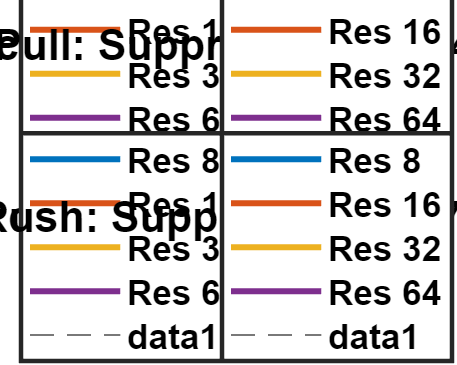

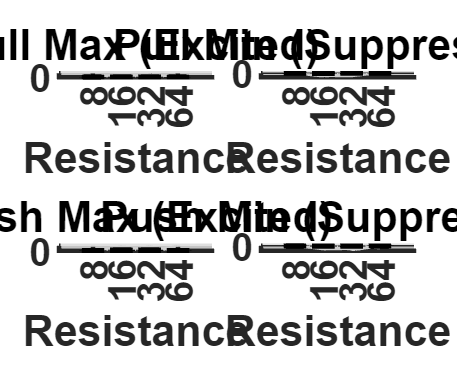

Plotting Downsampled Resistance ETA (Trial-count matched)...


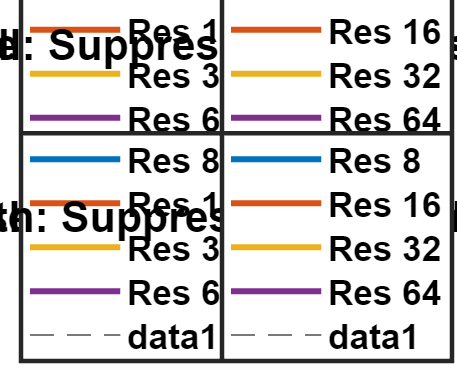

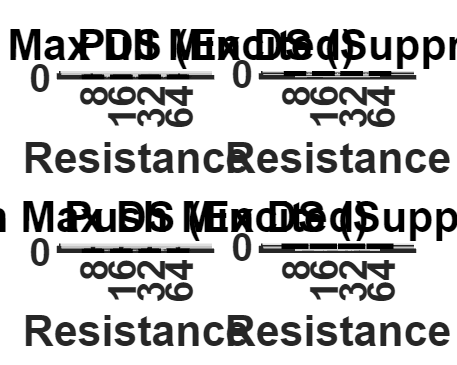

% =========================================================================
% Animal-based Resistance ETA Analysis (Hierarchical)
% =========================================================================
if inside_trial_eta == 2
    fprintf('\n========== Animal-based Resistance Analysis ==========\n');
    
    num_res = 4;
    res_vals = [8, 16, 32, 64];
    colors = [0 0.4470 0.7410; 0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.4940 0.1840 0.5560];
    res_labels = {'Res 8', 'Res 16', 'Res 32', 'Res 64'};
    time_len = fps * (before_event + after_event) + 1;
    
    % Animalごとの平均波形と統計値を格納する配列
    % [Animal x Resistance x Time]
    pull_up_traces = nan(length(Animal), num_res, time_len);
    pull_down_traces = nan(length(Animal), num_res, time_len);
    push_up_traces = nan(length(Animal), num_res, time_len);
    push_down_traces = nan(length(Animal), num_res, time_len);
    
    % [Animal x Resistance]
    pull_up_max = nan(length(Animal), num_res);
    pull_down_min = nan(length(Animal), num_res);
    push_up_max = nan(length(Animal), num_res);
    push_down_min = nan(length(Animal), num_res);

    pull_up_traces_ds = nan(length(Animal), num_res, time_len);
    pull_down_traces_ds = nan(length(Animal), num_res, time_len);
    push_up_traces_ds = nan(length(Animal), num_res, time_len);
    push_down_traces_ds = nan(length(Animal), num_res, time_len);
    
    pull_up_max_ds = nan(length(Animal), num_res);
    pull_down_min_ds = nan(length(Animal), num_res);
    push_up_max_ds = nan(length(Animal), num_res);
    push_down_min_ds = nan(length(Animal), num_res);   

    for i_animal = 1:length(Animal)
        % 1. インデックス抽出
        force_idx = force_idx_sessions{i_animal};
        force_idx2 = force_idx2_sessions{i_animal};
        trial = trial_sessions{i_animal};
        pullRes = pullResistance_sessions{i_animal};
        pushRes = pushResistance_sessions{i_animal};
        
        pull_indices = cell(1,4); push_indices = cell(1,4);
        
        for j = 1:length(force_idx)
            idx = force_idx(j);
            % イベント直後のフレームから該当するトライアル番号を取得
            t_idx = min(idx+fps, length(trial));
            t = max(trial(idx:t_idx));
            if t > 0 && t <= length(pullRes)
                r = pullRes(t);
                res_id = find(res_vals == r);
                if ~isempty(res_id), pull_indices{res_id} = [pull_indices{res_id}; idx]; end
            end
        end
        for j = 1:length(force_idx2)
            idx = force_idx2(j);
            t_idx = min(idx+fps, length(trial));
            t = max(trial(idx:t_idx));
            if t > 0 && t <= length(pushRes)
                r = pushRes(t);
                res_id = find(res_vals == r);
                if ~isempty(res_id), push_indices{res_id} = [push_indices{res_id}; idx]; end
            end
        end

        pull_indices_ds = cell(1,4); push_indices_ds = cell(1,4);
        min_pull = min(cellfun(@length, pull_indices)); % 4つの抵抗値の中の最小トライアル数
        min_push = min(cellfun(@length, push_indices));
        
        for k = 1:4
            if min_pull > 0
                idx_perm = randperm(length(pull_indices{k}), min_pull);
                pull_indices_ds{k} = pull_indices{k}(idx_perm);
            else
                pull_indices_ds{k} = []; % 1つでも0トライアルの条件があれば全て空(NaN)にする
            end
            
            if min_push > 0
                idx_perm = randperm(length(push_indices{k}), min_push);
                push_indices_ds{k} = push_indices{k}(idx_perm);
            else
                push_indices_ds{k} = [];
            end
        end
        
        % 2. 波形切り出し
        pull_res_acts = cell(1,4); push_res_acts = cell(1,4);
        pull_res_acts_ds = cell(1,4); push_res_acts_ds = cell(1,4);
        for k = 1:4
            pull_res_acts{k} = extract_event_activity(pull_indices{k}, acc_neural_activity_data_all_sessions{i_animal}, fps, before_event, after_event);
            push_res_acts{k} = extract_event_activity(push_indices{k}, acc_neural_activity_data_all_sessions{i_animal}, fps, before_event, after_event);

            pull_res_acts_ds{k} = extract_event_activity(pull_indices_ds{k}, acc_neural_activity_data_all_sessions{i_animal}, fps, before_event, after_event);
            push_res_acts_ds{k} = extract_event_activity(push_indices_ds{k}, acc_neural_activity_data_all_sessions{i_animal}, fps, before_event, after_event);
        end

        % 3. 有意細胞のインデックス取得
        sigs = sig_cell_idxs_sessions{i_animal};
        num_c = size(acc_neural_activity_data_all_sessions{i_animal}, 2);
        if norm == 7 && length(sigs) >= 18
            idx_pull_up   = sigs{15} == 1; 
            idx_pull_down = sigs{16} == 1;
            idx_push_up   = sigs{17} == 1; 
            idx_push_down = sigs{18} == 1;
        else
            idx_pull_up = true(1, num_c); idx_pull_down = true(1, num_c);
            idx_push_up = true(1, num_c); idx_push_down = true(1, num_c);
        end
        
        % 4. ローカルZスコア化とAnimalごとの平均、Max/Min計算
        for k = 1:4
            [tr, mx, ~] = calc_animal_stats(pull_res_acts{k}, idx_pull_up, fps, before_event, time_len);
            pull_up_traces(i_animal, k, :) = tr; pull_up_max(i_animal, k) = mx;
            
            [tr, ~, mn] = calc_animal_stats(pull_res_acts{k}, idx_pull_down, fps, before_event, time_len);
            pull_down_traces(i_animal, k, :) = tr; pull_down_min(i_animal, k) = mn;
            
            [tr, mx, ~] = calc_animal_stats(push_res_acts{k}, idx_push_up, fps, before_event, time_len);
            push_up_traces(i_animal, k, :) = tr; push_up_max(i_animal, k) = mx;
            
            [tr, ~, mn] = calc_animal_stats(push_res_acts{k}, idx_push_down, fps, before_event, time_len);
            push_down_traces(i_animal, k, :) = tr; push_down_min(i_animal, k) = mn;
        
            [tr, mx, ~] = calc_animal_stats(pull_res_acts_ds{k}, idx_pull_up, fps, before_event, time_len);
            pull_up_traces_ds(i_animal, k, :) = tr; pull_up_max_ds(i_animal, k) = mx;
            
            [tr, ~, mn] = calc_animal_stats(pull_res_acts_ds{k}, idx_pull_down, fps, before_event, time_len);
            pull_down_traces_ds(i_animal, k, :) = tr; pull_down_min_ds(i_animal, k) = mn;
            
            [tr, mx, ~] = calc_animal_stats(push_res_acts_ds{k}, idx_push_up, fps, before_event, time_len);
            push_up_traces_ds(i_animal, k, :) = tr; push_up_max_ds(i_animal, k) = mx;
            
            [tr, ~, mn] = calc_animal_stats(push_res_acts_ds{k}, idx_push_down, fps, before_event, time_len);
            push_down_traces_ds(i_animal, k, :) = tr; push_down_min_ds(i_animal, k) = mn;
        end
    end
    
    % --- Plot 1: Split Population Average (Animal-based) ---
    time_axis = -before_event:0.1:after_event;
    figure('Name', 'Resistance Avg (Animal Mean Split)', 'Color', 'w', 'Position', [50, 50, 1000, 800]);
    plot_animal_avg_helper = @(traces, ax_idx, title_str) ...
        plot_animal_avg(traces, time_axis, colors, res_labels, ax_idx, title_str);
    
    plot_animal_avg_helper(pull_up_traces, 1, 'Pull: Excited');
    plot_animal_avg_helper(pull_down_traces, 2, 'Pull: Suppressed');
    plot_animal_avg_helper(push_up_traces, 3, 'Push: Excited');
    plot_animal_avg_helper(push_down_traces, 4, 'Push: Suppressed');
    saveas(gcf, [output_dir 'Animal_resistance_avg_split.png']);
    
    % --- Plot 3: Stats (Animal-wise Max/Min) ---
    figure('Name', 'Resistance Stats (Animal-wise)', 'Color', 'w', 'Position', [50, 50, 1000, 800]);
    subplot(2,2,1); plot_stats_internal(pull_up_max, {'8','16','32','64'}, 'Pull Max (Excited)');
    subplot(2,2,2); plot_stats_internal(pull_down_min, {'8','16','32','64'}, 'Pull Min (Suppressed)');
    subplot(2,2,3); plot_stats_internal(push_up_max, {'8','16','32','64'}, 'Push Max (Excited)');
    subplot(2,2,4); plot_stats_internal(push_down_min, {'8','16','32','64'}, 'Push Min (Suppressed)');
    saveas(gcf, [output_dir 'Animal_resistance_stats_split.png']);

    fprintf('Plotting Downsampled Resistance ETA (Trial-count matched)...\n');
    
    % Plot 1 DS: Split Population Average
    figure('Name', 'Resistance Avg DS (Animal Mean Split)', 'Color', 'w', 'Position', [100, 100, 1000, 800]);
    
    plot_animal_avg_helper(pull_up_traces_ds, 1, 'Pull: Excited (DS)');
    plot_animal_avg_helper(pull_down_traces_ds, 2, 'Pull: Suppressed (DS)');
    plot_animal_avg_helper(push_up_traces_ds, 3, 'Push: Excited (DS)');
    plot_animal_avg_helper(push_down_traces_ds, 4, 'Push: Suppressed (DS)');
    saveas(gcf, [output_dir 'Animal_resistance_avg_split_DS.png']);
    
    % Plot 3 DS: Stats (Animal-wise Max/Min)
    figure('Name', 'Resistance Stats DS (Animal-wise)', 'Color', 'w', 'Position', [100, 100, 1000, 800]);
    subplot(2,2,1); plot_stats_internal(pull_up_max_ds, {'8','16','32','64'}, 'Pull Max DS (Excited)');
    subplot(2,2,2); plot_stats_internal(pull_down_min_ds, {'8','16','32','64'}, 'Pull Min DS (Suppressed)');
    subplot(2,2,3); plot_stats_internal(push_up_max_ds, {'8','16','32','64'}, 'Push Max DS (Excited)');
    subplot(2,2,4); plot_stats_internal(push_down_min_ds, {'8','16','32','64'}, 'Push Min DS (Suppressed)');
    saveas(gcf, [output_dir 'Animal_resistance_stats_split_DS.png']);
end

if norm == 7
    fprintf('\n========== Plotting Overlapped ETA (Poster Format) ==========\n');
    
    % --- パラメータ設定 ---
    time_axis = -before_event : (1/fps) : after_event;
    
    % 4つのパネルの定義 (Pull用Index, Push用Index, 表示ラベル)
    panel_defs = {
        11, 13, 'Pre-Activation';
        15, 17, 'Post-Activation';
        12, 14, 'Pre-Suppression';
        16, 18, 'Post-Suppression'
    };

    % カラー設定 (ポスター用の鮮やかな色)
    color_pull = [0.00 0.45 0.74]; % 青
    color_push = [0.85 0.33 0.10]; % 赤
    
    figure('Name', 'Overlapped Directional ETA', 'Color', 'w', 'Position', [50, 50, 1000, 850]);
    
    for p = 1:4
        pull_sig_id = panel_defs{p, 1};
        push_sig_id = panel_defs{p, 2};
        label_str   = panel_defs{p, 3};
        
        all_pull_traces = [];
        all_push_traces = [];
        
        for i_animal = 1:length(Animal)
            sigs = sig_cell_idxs_sessions{i_animal};
            if isempty(sigs) || length(sigs) < 18, continue; end
            
            % このパネルの対象細胞 (PullまたはPushのどちらかに反応した細胞)
            sig_mask = (sigs{pull_sig_id} == 1 | sigs{push_sig_id} == 1);
            if sum(sig_mask) == 0, continue; end
            
            % データの抽出
            raw_pull = extract_event_activity(force_idx_sessions{i_animal}, acc_neural_activity_data_all_sessions{i_animal}, fps, before_event, after_event);
            raw_push = extract_event_activity(force_idx2_sessions{i_animal}, acc_neural_activity_data_all_sessions{i_animal}, fps, before_event, after_event);
            
            % Zスコア正規化 (セッション内ベースライン基準)
            idx_base = 1 : (fps * before_event);
            % Pull用
            mu_b1 = mean(raw_pull(:, idx_base, :), [2 3], 'omitnan');
            sd_b1 = std(raw_pull(:, idx_base, :), 0, [2 3], 'omitnan');
            pull_avg = mean((raw_pull - mu_b1) ./ (sd_b1 + 1e-6), 3, 'omitnan');
            
            % Push用
            mu_b2 = mean(raw_push(:, idx_base, :), [2 3], 'omitnan');
            sd_b2 = std(raw_push(:, idx_base, :), 0, [2 3], 'omitnan');
            push_avg = mean((raw_push - mu_b2) ./ (sd_b2 + 1e-6), 3, 'omitnan');
            
            % マスクに該当する細胞を蓄積
            all_pull_traces = [all_pull_traces; pull_avg(sig_mask, :)];
            all_push_traces = [all_push_traces; push_avg(sig_mask, :)];
        end
        
        % --- プロット描画 ---
        subplot(2, 2, p); hold on;
        
        if ~isempty(all_pull_traces)
            % Pull プロット (Blue)
            mu1 = mean(all_pull_traces, 1, 'omitnan');
            sem1 = std(all_pull_traces, 0, 1, 'omitnan') ./ sqrt(size(all_pull_traces, 1));
            fill([time_axis, fliplr(time_axis)], [mu1+sem1, fliplr(mu1-sem1)], color_pull, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
            plot(time_axis, mu1, 'Color', color_pull, 'LineWidth', 4);
            
            % Push プロット (Red)
            mu2 = mean(all_push_traces, 1, 'omitnan');
            sem2 = std(all_push_traces, 0, 1, 'omitnan') ./ sqrt(size(all_push_traces, 1));
            fill([time_axis, fliplr(time_axis)], [mu2+sem2, fliplr(mu2-sem2)], color_push, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
            plot(time_axis, mu2, 'Color', color_push, 'LineWidth', 4);
        end
        
        % --- ポスター用装飾 (グリッド・n数削除) ---
        title(label_str, 'FontSize', 26, 'FontWeight', 'bold', 'Margin', 10);
        xline(0, 'k-', 'LineWidth', 2);
        box off; % グリッド削除済み (デフォルトoff)
        set(gca, 'FontSize', 22, 'LineWidth', 2, 'TickDir', 'out', 'XGrid', 'off', 'YGrid', 'off');
        
        xlim([-before_event after_event]);
        if p > 2, xlabel('Time from Onset (s)', 'FontSize', 24, 'FontWeight', 'bold'); end
        if mod(p, 2) == 1, ylabel('Activity (Z-score)', 'FontSize', 24, 'FontWeight', 'bold'); end
        
        % Y軸範囲の固定
        if p <= 2, ylim([-0.2 0.2]); else, ylim([-0.2 0.2]); end
        
        % 凡例 (右上のパネルのみ)
        if p == 4
            legend({'Pull', 'Push'}, 'Location', 'northeastoutside', 'FontSize', 22, 'Box', 'off');
        end
    end
    
    saveas(gcf, [output_dir 'Overlapped_8Type_ETA_Poster.png']);
end

%% --皮質BTSP仮説を検証するための解析 (複数セッション統合版)--

if GLM_HMM
    disp('=== GLM-HMM 多重セッション統合解析を開始します ===');
    
    % --- 1. GLM-HMM データの読み込みとセッション数チェック ---
    % ※ CSVのパスは環境に合わせて調整してください。ここでは1番目の動物のフォルダを使用します。
    glm_hmm_file = [strjoin(data_folders(1)) filesep 'glm_hmm_states_all_sessions.csv']; 
    if ~isfile(glm_hmm_file)
        error('エラー: 指定されたパスに glm_hmm_states_all_sessions.csv が見つかりません。パスを確認してください。');
    end
    
    glm_hmm_data = readtable(glm_hmm_file);
    unique_glm_sessions = unique(glm_hmm_data.Session_ID);
    num_glm_sessions = length(unique_glm_sessions);
    num_neural_sessions = length(Animal);
    
    % セッション数の一致確認
    if num_glm_sessions ~= num_neural_sessions
        error('エラー: GLM-HMMのセッション数 (%d) と 神経データのセッション数 (%d) が一致しません。', num_glm_sessions, num_neural_sessions);
    end
    disp(['全 ' num2str(num_neural_sessions) ' セッションの同期性解析を実行します...']);

    % --- 2. 統合データ保存用変数の初期化 ---
    % 全細胞の分布用 (CDF/ヒストグラム用)
    all_taus_L23 = []; all_taus_L5 = [];
    all_lags_L23 = []; all_lags_L5 = [];
    
    % セッションごとの中央値用 (散布図/検定用)
    median_tau_L23 = NaN(1, num_neural_sessions);
    median_tau_L5  = NaN(1, num_neural_sessions);
    median_lag_L23 = NaN(1, num_neural_sessions);
    median_lag_L5  = NaN(1, num_neural_sessions);
    % 記録用変数の初期化 (セッションごとの割合)
    prop_abrupt_L23 = NaN(1, num_neural_sessions);
    prop_abrupt_L5  = NaN(1, num_neural_sessions);
    prop_sync_L23 = NaN(1, num_neural_sessions);
    prop_sync_L5  = NaN(1, num_neural_sessions);

    % 解析パラメータの設定
    cp_min_distance = 20; %40;
    cp_max_changes = 4; %3; 
    fit_window = 20;
    sigmoid_fun = @(p, x) p(1) + p(2) ./ (1 + exp(-(x - p(3)) ./ p(4)));
    options = optimoptions('lsqcurvefit', 'Display', 'off');
    abrupt_threshold = 0.5; % τ < 0.5 を「急峻な変化」と定義
    sync_threshold = 5; % |Lag| <= 5トライアルを「同期」と定義

    num_shuffles = 1000; % シャッフル回数
    total_sync_L23_real = 0; 
    total_sync_L5_real  = 0;
    total_sync_L23_shuffled = zeros(1, num_shuffles);
    total_sync_L5_shuffled  = zeros(1, num_shuffles);  
    
    % --- 3. セッションごとのループ処理 ---
    for i_sess = 1:num_neural_sessions
        disp(['>> Session ' num2str(i_sess) ' (' strjoin(Animal(i_sess)) ') を解析中...']);
        
        % (A) 行動の変化点を「実際のトライアル番号」ベースで取得
        session_glm_data = glm_hmm_data(glm_hmm_data.Session_ID == unique_glm_sessions(i_sess), :);
        % CSVの行番号ではなく、列「Trial_Number」などを使って変化点を記録する
        behavioral_change_points = session_glm_data.Trial_ID(find(diff(session_glm_data.Max_State) ~= 0) + 1);
        
        % (B) 神経データの準備 (細胞のレイヤー情報をロード)
        mat_file_path = [strjoin(data_folders(i_sess)) filesep strjoin(Animal(i_sess)) '_neural_activity_' strjoin(Date(i_sess)) '_' strjoin(Key(i_sess)) '.mat'];
        tmp_data = load(mat_file_path, 'pointAreas');
        pointAreas_sess = tmp_data.pointAreas; % 1: L2/3, 0: L5   

        neural_data_continuous = acc_neural_activity_data_all_sessions{i_sess};
        sig_idxs_sess = sig_cell_idxs_sessions{i_sess};
        
        event_names = {'Pull', 'Push'};
        event_idx_lists = {force_idx_sessions{i_sess}, force_idx2_sessions{i_sess}};
        event_sigs_lists = {sig_idxs_sess{4}, sig_idxs_sess{6}}; % 4:Pull, 6:Push

        % そのセッションの各レイヤーの「全細胞数」をカウント
        total_L23_in_sess = sum(pointAreas_sess == 1);
        total_L5_in_sess  = sum(pointAreas_sess == 0);
        
        % 急峻な変化を起こした「ユニークな細胞」を記録するためのフラグ
        is_abrupt_cell = false(1, length(pointAreas_sess));  
        is_sync_cell   = false(1, length(pointAreas_sess)); % 同期フラグ

        sess_taus_L23 = []; sess_taus_L5 = [];
        sess_lags_L23 = []; sess_lags_L5 = [];

        % --- PullとPushのどちらかで有意な細胞をすべて取得 (重複なし) ---
        pull_idxs = event_idx_lists{1};
        push_idxs = event_idx_lists{2};
        sig_pull_idx = event_sigs_lists{1};
        sig_push_idx = event_sigs_lists{2};
        
        sig_cells = unique([find(sig_pull_idx == 1), find(sig_push_idx == 1)]);
        num_sig_cells = length(sig_cells);
        
        trial_info = trial_sessions{i_sess}; % [Time x 1] のトライアル番号配列
        num_total_trials = max(trial_info);
        
        for i_cell = 1:num_sig_cells
            cell_idx_global = sig_cells(i_cell);
            layer_label = pointAreas_sess(cell_idx_global);
            
            % 1. 全トライアルの応答を保持する配列 (NaNで初期化)
            trace_full = NaN(1, num_total_trials);
            
            % 2. Pullの応答を配置 (同トライアル内に複数あれば最大値をとる)
            if ~isempty(pull_idxs)
                for tr = 1:length(pull_idxs)
                    start_idx = pull_idxs(tr);
                    end_idx = start_idx + fps;
                    safe_end_idx = min(end_idx, length(trial_info));
                    t = max(trial_info(start_idx:safe_end_idx)); % グローバルトライアル番号を取得
                    
                    if end_idx <= size(neural_data_continuous, 1) && t > 0
                        resp = mean(neural_data_continuous(start_idx:end_idx, cell_idx_global));
                        trace_full(t) = max([trace_full(t), resp], [], 'omitnan');
                    end
                end
            end
            
            % 3. Pushの応答を配置 (Pullと重複するトライアルは最大値をとる)
            if ~isempty(push_idxs)
                for tr = 1:length(push_idxs)
                    start_idx = push_idxs(tr);
                    end_idx = start_idx + fps;
                    safe_end_idx = min(end_idx, length(trial_info));
                    t = max(trial_info(start_idx:safe_end_idx)); % グローバルトライアル番号を取得
                    
                    if end_idx <= size(neural_data_continuous, 1) && t > 0
                        resp = mean(neural_data_continuous(start_idx:end_idx, cell_idx_global));
                        trace_full(t) = max([trace_full(t), resp], [], 'omitnan');
                    end
                end
            end
            
            % 4. 欠損値を飛ばした実データのみを抽出 (線形補完はしない)
            valid_trials = find(~isnan(trace_full));
            if isempty(valid_trials), continue; end
            trace_valid = trace_full(valid_trials);
            
            % --- 変化点検知 ---
            try
                [ipts, ~] = findchangepts(trace_valid, 'Statistic', 'mean', ...
                    'MinDistance', cp_min_distance, 'MaxNumChanges', cp_max_changes);
            catch
                continue;
            end
            
            for c = 1:length(ipts)
                cp = ipts(c);
                idx_start = max(1, cp - fit_window);
                idx_end = min(length(trace_valid), cp + fit_window);
                
                local_x_global = valid_trials(idx_start:idx_end); % X軸は実際の全体トライアル番号
                local_y = trace_valid(idx_start:idx_end);
                
                % S/N比チェック (基準を 2* に緩和してあります)
                amp_guess = mean(local_y(end-9:end)) - mean(local_y(1:10));
                baseline_std = std(local_y(1:10));
                if amp_guess <= 2 * (baseline_std+1e-4), continue; end
                
                base_guess = mean(local_y(1:3));
                cp_global = valid_trials(cp);
                window_width_global = local_x_global(end) - local_x_global(1);
                p0 = [base_guess, amp_guess, cp_global, 4.0];
                
                lb = [min(local_y)-abs(amp_guess), 0,   cp_global - window_width_global/2, 0.1];
                ub = [max(local_y)+abs(amp_guess), inf, cp_global + window_width_global/2, window_width_global];
                
                try
                    p_fit = lsqcurvefit(sigmoid_fun, p0, local_x_global, local_y, lb, ub, options);
                    
                    fitted_tau = p_fit(4);
                    fitted_amp = p_fit(2);
                    fitted_t0_global  = p_fit(3); % ここが完全に全体トライアル軸の座標になります
                    
                    if fitted_tau < abrupt_threshold
                        is_abrupt_cell(cell_idx_global) = true;
                    end     
                    
                    % Lagの計算 (Global同士の比較になるため正確)
                    if isempty(behavioral_change_points)
                        lag_val = NaN;
                    else
                        [~, min_idx] = min(abs(behavioral_change_points - fitted_t0_global));
                        lag_val = fitted_t0_global - behavioral_change_points(min_idx);
                        
                        % 極端に離れた変化点（別イベントの誤検知等）は除外
                        if abs(lag_val) > 20
                            continue; 
                        end                    
                        if abs(lag_val) <= sync_threshold
                            is_sync_cell(cell_idx_global) = true;
                        end
                    end
                    
                    % セッション内の記録用配列に格納
                    if layer_label == 1
                        sess_taus_L23(end+1) = fitted_tau;
                        sess_lags_L23(end+1) = lag_val;
                        all_taus_L23(end+1) = fitted_tau;
                        all_lags_L23(end+1) = lag_val;
                    else
                        sess_taus_L5(end+1) = fitted_tau;
                        sess_lags_L5(end+1) = lag_val;
                        all_taus_L5(end+1) = fitted_tau;
                        all_lags_L5(end+1) = lag_val;
                    end
                    
                catch
                    continue;
                end
            end % 変化点のループ
        end % 細胞のループ

        % % PullとPushでループ
        % for ev = 1:2
        %     ev_idxs = event_idx_lists{ev};
        %     sig_target_idx = event_sigs_lists{ev};
        % 
        %     if isempty(ev_idxs) || sum(sig_target_idx) == 0
        %         continue;
        %     end
        % 
        %     sig_cells = find(sig_target_idx == 1);
        %     num_sig_cells = length(sig_cells);
        %     num_trials_target = length(ev_idxs);
        %     trial_responses = zeros(num_sig_cells, num_trials_target);
        %     trial_mapping = zeros(1, num_trials_target);
        %     trial_info = trial_sessions{i_sess}; % [Time x 1] のトライアル番号配列
        % 
        %     % メモリ節約のため、連続データからイベント後(post)の応答を直接抽出
        %     for tr = 1:num_trials_target
        %         start_idx = ev_idxs(tr);
        %         end_idx = start_idx + fps; % 1秒間のpost window
        %         safe_end_idx = min(end_idx, length(trial_info));
        %         actual_trial_num = max(trial_info(start_idx:safe_end_idx));
        %         trial_mapping(tr) = actual_trial_num;
        %         if end_idx <= size(neural_data_continuous, 1)
        %             % 該当トライアルの有意細胞の平均応答を計算
        %             trial_responses(:, tr) = mean(neural_data_continuous(start_idx:end_idx, sig_cells), 1)';
        %         else
        %             trial_responses(:, tr) = NaN;
        %         end
        %     end
        % 
        %     % 変化点検知とシグモイドフィット
        %     for i_cell = 1:num_sig_cells
        %         trace = trial_responses(i_cell, :);
        %         if any(isnan(trace)), continue; end
        % 
        %         cell_idx_global = sig_cells(i_cell);
        %         layer_label = pointAreas_sess(cell_idx_global);
        % 
        %         % 変化点を探す
        %         try
        %             [ipts, ~] = findchangepts(trace, 'Statistic', 'mean', ...
        %                 'MinDistance', cp_min_distance, 'MaxNumChanges', cp_max_changes);
        %         catch
        %             continue; % 十分なデータ点がない場合など
        %         end
        % 
        %         for c = 1:length(ipts)
        %             cp = ipts(c);
        %             idx_start = max(1, cp - fit_window);
        %             idx_end = min(length(trace), cp + fit_window);
        %             local_x = idx_start:idx_end;
        %             local_y = trace(local_x);
        % 
        %             amp_guess = mean(local_y(end-9:end)) - mean(local_y(1:10));
        %             baseline_std = std(local_y(1:10));
        %             if amp_guess <= 3 * (baseline_std+1e-4), continue; end
        %             % if amp_guess <= 0.05, continue; end % 活性化方向のみ
        % 
        %             base_guess = mean(local_y(1:3));
        %             p0 = [base_guess, amp_guess, cp, 2.0];
        %             lb = [min(local_y)-abs(amp_guess), 0,   cp - fit_window/2, 0.1];
        %             ub = [max(local_y)+abs(amp_guess), inf, cp + fit_window/2, 20];
        % 
        %             try
        %                 p_fit = lsqcurvefit(sigmoid_fun, p0, local_x, local_y, lb, ub, options);
        %                 fitted_tau = p_fit(4);
        %                 fitted_amp = p_fit(2);
        %                 fitted_t0  = p_fit(3);
        % 
        %                 if fitted_amp < 1e-3, continue; end
        % 
        %                 if fitted_tau < abrupt_threshold
        %                     is_abrupt_cell(cell_idx_global) = true;
        %                 end     
        %                 % ★ 変更: fitted_t0 (配列上の位置) を、実際のトライアル番号に変換
        %                 % 小数点（例: 45.3番目）も線形補間で正確なトライアル番号（例: 52.7番）に直す
        %                 fitted_t0_abs = interp1(1:num_trials_target, trial_mapping, fitted_t0, 'linear', 'extrap');
        %                 % Lagの計算
        %                 if isempty(behavioral_change_points)
        %                     lag_val = NaN;
        %                 else
        %                     [~, min_idx] = min(abs(behavioral_change_points - fitted_t0_abs));
        %                     lag_val = fitted_t0_abs - behavioral_change_points(min_idx);
        %                     if abs(lag_val) > 20
        %                         continue; 
        %                     end                    
        %                     if abs(lag_val) <= sync_threshold
        %                         is_sync_cell(cell_idx_global) = true;
        %                     end
        %                 end
        % 
        %                 % セッション内の変数に記録
        %                 if layer_label == 1
        %                     sess_taus_L23(end+1) = fitted_tau;
        %                     sess_lags_L23(end+1) = lag_val;
        %                 else
        %                     sess_taus_L5(end+1) = fitted_tau;
        %                     sess_lags_L5(end+1) = lag_val;
        %                 end
        % 
        %                 % 全細胞の蓄積変数に記録
        %                 if layer_label == 1
        %                     all_taus_L23(end+1) = fitted_tau;
        %                     all_lags_L23(end+1) = lag_val;
        %                 else
        %                     all_taus_L5(end+1) = fitted_tau;
        %                     all_lags_L5(end+1) = lag_val;
        %                 end
        % 
        %             catch
        %                 continue;
        %             end
        %         end % 変化点のループ
        %     end % 細胞のループ
        % end % イベント(Pull/Push)のループ
        
        % (C) セッションごとの中央値を計算して記録
        if ~isempty(sess_taus_L23), median_tau_L23(i_sess) = median(sess_taus_L23, 'omitnan'); end
        if ~isempty(sess_taus_L5),  median_tau_L5(i_sess)  = median(sess_taus_L5, 'omitnan');  end
        if ~isempty(sess_lags_L23), median_lag_L23(i_sess) = median(sess_lags_L23, 'omitnan'); end
        if ~isempty(sess_lags_L5),  median_lag_L5(i_sess)  = median(sess_lags_L5, 'omitnan');  end
        prop_abrupt_L23(i_sess) = sum(is_abrupt_cell & (pointAreas_sess' == 1)) / total_L23_in_sess;
        prop_abrupt_L5(i_sess)  = sum(is_abrupt_cell & (pointAreas_sess' == 0)) / total_L5_in_sess; 
        prop_sync_L23(i_sess) = sum(is_sync_cell & (pointAreas_sess' == 1)) / total_L23_in_sess;
        prop_sync_L5(i_sess)  = sum(is_sync_cell & (pointAreas_sess' == 0)) / total_L5_in_sess;

        % --- ↓ 追加・修正: (D) シャッフル検定 (全セッション統合用カウント) ↓ ---
        % 実際の同期細胞数を加算
        total_sync_L23_real = total_sync_L23_real + sum(is_sync_cell & (pointAreas_sess' == 1));
        total_sync_L5_real  = total_sync_L5_real  + sum(is_sync_cell & (pointAreas_sess' == 0));

        if ~isempty(behavioral_change_points)
            min_trial = min(trial_info); max_trial = max(trial_info);
            num_fitted_L23 = length(sess_lags_L23);
            num_fitted_L5  = length(sess_lags_L5);
            bcp_vec = behavioral_change_points(:);
            
            for iter = 1:num_shuffles
                if num_fitted_L23 > 0
                    rand_t0_L23 = min_trial + (max_trial - min_trial) * rand(1, num_fitted_L23);
                    min_abs_lags_L23 = min(abs(bcp_vec - rand_t0_L23), [], 1);
                    total_sync_L23_shuffled(iter) = total_sync_L23_shuffled(iter) + sum(min_abs_lags_L23 <= sync_threshold);
                end
                if num_fitted_L5 > 0
                    rand_t0_L5 = min_trial + (max_trial - min_trial) * rand(1, num_fitted_L5);
                    min_abs_lags_L5 = min(abs(bcp_vec - rand_t0_L5), [], 1);
                    total_sync_L5_shuffled(iter) = total_sync_L5_shuffled(iter) + sum(min_abs_lags_L5 <= sync_threshold);
                end
            end
        end  
    end % セッションループ終了
    p_val_shuffle_global_L23 = (sum(total_sync_L23_shuffled >= total_sync_L23_real) + 1) / (num_shuffles + 1);
    p_val_shuffle_global_L5  = (sum(total_sync_L5_shuffled  >= total_sync_L5_real) + 1)  / (num_shuffles + 1);
    
    fprintf('=== 全セッション統合 シャッフル検定結果 ===\n');
    fprintf('L2/3: p = %.4f\n', p_val_shuffle_global_L23);
    fprintf('L5  : p = %.4f\n\n', p_val_shuffle_global_L5);   
    disp('解析完了。可視化と統計検定を実行します...');
    
    % NaNを除外した全細胞Lag
    all_lags_L23_valid = all_lags_L23(~isnan(all_lags_L23));
    all_lags_L5_valid  = all_lags_L5(~isnan(all_lags_L5));

    %% --- 4. 結果の可視化と統計検定 ---
    
    % ==========================================
    % Figure: 全細胞レベルでの分布 (CDF & Hist)
    % ==========================================
    hFigAll = figure('Name', 'All Cells: Dynamics (L2/3 vs L5)', 'Position', [100, 100, 1000, 400], 'Color', 'w');
    
    % --- サブプロット1: タイムラグ (Lag) のヒストグラム (全細胞) ---
    subplot(1, 2, 1); hold on;
    edges = -20:2:20;
    if ~isempty(all_lags_L23_valid), histogram(all_lags_L23_valid, edges, 'FaceColor', [0 0.7 0], 'FaceAlpha', 0.5, 'Normalization', 'probability', 'DisplayName', 'Layer 2/3'); end
    if ~isempty(all_lags_L5_valid),  histogram(all_lags_L5_valid, edges, 'FaceColor', [0 0.4 0.8], 'FaceAlpha', 0.5, 'Normalization', 'probability', 'DisplayName', 'Layer 5'); end
    xline(0, 'r--', 'LineWidth', 2, 'DisplayName', 'Behavioral Change');
    ylims = ylim; 
    text_y_pos = ylims(2) * 0.95; % グラフ上部から描画
    if p_val_shuffle_global_L23 < 0.05
        text(-19, text_y_pos, sprintf('L2/3 Sync: p=%.3f *', p_val_shuffle_global_L23), 'Color', [0 0.5 0], 'FontWeight', 'bold');
        text_y_pos = text_y_pos - ylims(2) * 0.08; % 次のテキストを下へずらす
    end
    if p_val_shuffle_global_L5 < 0.05
        text(-19, text_y_pos, sprintf('L5 Sync: p=%.3f *', p_val_shuffle_global_L5), 'Color', [0 0.3 0.7], 'FontWeight', 'bold');
    end
    hold off;
    xlabel('Lag: \Delta t_{neu} - t_{beh} (Trials)'); ylabel('Probability');
    title('All Cells: Sync with Behavioral Strategy'); legend('Location', 'northeast'); grid on; box off;

    % --- サブプロット2: 急峻さ (Tau) のCDF (全細胞) ---
    subplot(1, 2, 2); hold on;
    if ~isempty(all_taus_L23)
        [f1, x1] = ecdf(all_taus_L23);
        plot(x1, f1, 'Color', [0 0.7 0], 'LineWidth', 2, 'DisplayName', 'Layer 2/3');
    end
    if ~isempty(all_taus_L5)
        [f2, x2] = ecdf(all_taus_L5);
        plot(x2, f2, 'Color', [0 0.4 0.8], 'LineWidth', 2, 'DisplayName', 'Layer 5');
    end
    hold off;
    
    % X軸を対数軸に設定
    set(gca, 'XScale', 'log'); 
    % 0.1から20程度（シグモイドフィットの境界条件）に範囲を調整
    xlim([0.1, 20]); 
    
    % 目盛りを読みやすく設定（任意で調整してください）
    xticks([0.1, 0.2, 0.5, 1, 2, 5, 10, 20]);
    xticklabels({'0.1', '0.2', '0.5', '1', '2', '5', '10', '20'});

    xlabel('Transition Time Constant \tau (Trials, log scale)'); 
    ylabel('Cumulative Probability');
    title('All Cells: CDF of Transition Abruptness'); 
    legend('Location', 'southeast'); 
    grid on; box off;
    % ==========================================
    % Figure: セッション中央値の比較と統計検定
    % ==========================================
    % 検定の準備
    valid_tau_pairs = ~isnan(median_tau_L23) & ~isnan(median_tau_L5);
    valid_lag_pairs = ~isnan(median_lag_L23) & ~isnan(median_lag_L5);
    
    p_tau = NaN; p_lag = NaN;p_lag_signed = NaN;
    if sum(valid_tau_pairs) >= 3, p_tau = signrank(median_tau_L23(valid_tau_pairs), median_tau_L5(valid_tau_pairs)); end
    if sum(valid_lag_pairs) >= 3, p_lag = signrank(median_lag_L23(valid_lag_pairs), median_lag_L5(valid_lag_pairs)); end
    if sum(valid_lag_pairs) >= 3, p_lag_signed = signrank(median_lag_L23(valid_lag_pairs), median_lag_L5(valid_lag_pairs)); end

    % ハンドル hFigMedian に格納
    hFigMedian = figure('Name', 'Session Medians: L2/3 vs L5', 'Position', [150, 150, 800, 400], 'Color', 'w');
    
    % サブプロット1: セッション中央値のLag
    subplot(1, 3, 1); hold on;
    for i = 1:num_neural_sessions
        if valid_lag_pairs(i)
            plot([1, 2], [abs(median_lag_L23(i)), abs(median_lag_L5(i))], '-', 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
        end
    end
    plot_data_lag = [abs(median_lag_L23(valid_lag_pairs)), abs(median_lag_L5(valid_lag_pairs))];
    group_lag = [ones(1, sum(valid_lag_pairs)), 2*ones(1, sum(valid_lag_pairs))];
    if ~isempty(plot_data_lag)
        boxplot(plot_data_lag, group_lag, 'Labels', {'L2/3', 'L5'}, 'Colors', [0 0.7 0; 0 0.4 0.8], 'Symbol', '');
        scatter(ones(1, sum(valid_lag_pairs)), abs(median_lag_L23(valid_lag_pairs)), 50, [0 0.7 0], 'filled', 'MarkerEdgeColor', 'w');
        scatter(2*ones(1, sum(valid_lag_pairs)), abs(median_lag_L5(valid_lag_pairs)), 50, [0 0.4 0.8], 'filled', 'MarkerEdgeColor', 'w');
    end
    hold off;
    ylabel('Absolute Median Lag (Trials)'); title('Session Median: Absolute Lag'); box off;
    if ~isnan(p_lag), text(1.5, max(plot_data_lag)*1.05, ['p = ', num2str(p_lag, '%.3f')], 'HorizontalAlignment', 'center', 'FontWeight', 'bold'); end
    % --- 【追加】サブプロット2: セッション中央値のLag (正負そのまま) ---
    subplot(1, 3, 2); hold on;
    for i = 1:num_neural_sessions
        if valid_lag_pairs(i)
            plot([1, 2], [median_lag_L23(i), median_lag_L5(i)], '-', 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
        end
    end
    plot_data_lag_signed = [median_lag_L23(valid_lag_pairs), median_lag_L5(valid_lag_pairs)];
    group_lag_signed = [ones(1, sum(valid_lag_pairs)), 2*ones(1, sum(valid_lag_pairs))];
    if ~isempty(plot_data_lag_signed)
        boxplot(plot_data_lag_signed, group_lag_signed, 'Labels', {'L2/3', 'L5'}, 'Colors', [0 0.7 0; 0 0.4 0.8], 'Symbol', '');
        scatter(ones(1, sum(valid_lag_pairs)), median_lag_L23(valid_lag_pairs), 50, [0 0.7 0], 'filled', 'MarkerEdgeColor', 'w');
        scatter(2*ones(1, sum(valid_lag_pairs)), median_lag_L5(valid_lag_pairs), 50, [0 0.4 0.8], 'filled', 'MarkerEdgeColor', 'w');
    end
    yline(0, 'r--', 'LineWidth', 1.5, 'Alpha', 0.5); % 基準となる 0 (完全同期) のライン
    hold off;
    ylabel('Median Lag (Trials)'); title('Session Median: Signed Lag'); box off;
    if ~isnan(p_lag_signed)
        y_lims = get(gca, 'YLim'); % 負の値を含みうるため、テキスト位置をY軸の上限から相対的に計算
        text(1.5, y_lims(2) - 0.05*(y_lims(2)-y_lims(1)), ['p = ', num2str(p_lag_signed, '%.3f')], 'HorizontalAlignment', 'center', 'FontWeight', 'bold'); 
    end
    % サブプロット2: セッション中央値のTau
    subplot(1, 3, 3); hold on;
    for i = 1:num_neural_sessions
        if valid_tau_pairs(i)
            plot([1, 2], [median_tau_L23(i), median_tau_L5(i)], '-', 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
        end
    end
    plot_data_tau = [median_tau_L23(valid_tau_pairs), median_tau_L5(valid_tau_pairs)];
    group_tau = [ones(1, sum(valid_tau_pairs)), 2*ones(1, sum(valid_tau_pairs))];
    if ~isempty(plot_data_tau)
        boxplot(plot_data_tau, group_tau, 'Labels', {'L2/3', 'L5'}, 'Colors', [0 0.7 0; 0 0.4 0.8], 'Symbol', '');
        scatter(ones(1, sum(valid_tau_pairs)), median_tau_L23(valid_tau_pairs), 50, [0 0.7 0], 'filled', 'MarkerEdgeColor', 'w');
        scatter(2*ones(1, sum(valid_tau_pairs)), median_tau_L5(valid_tau_pairs), 50, [0 0.4 0.8], 'filled', 'MarkerEdgeColor', 'w');
    end
    hold off;
    ylabel('Median \tau (Trials)'); title('Session Median: Transition \tau'); box off;
    if ~isnan(p_tau), text(1.5, max(plot_data_tau)*1.05, ['p = ', num2str(p_tau, '%.3f')], 'HorizontalAlignment', 'center', 'FontWeight', 'bold'); end
    
    % --- 保存 ---
    if exist('output_dir', 'var')
        % 番号ではなくハンドルを指定して保存
        saveas(hFigAll, [output_dir 'MultiSess_AllCells_Dynamics.png']);
        saveas(hFigMedian, [output_dir 'MultiSess_Medians_Stats.png']);
        disp(['画像を保存しました: ' output_dir]);
    end

    % ==========================================
    % Figure 3: 細胞の割合の比較 (Abruptness & Synchrony)
    % ==========================================
    hFigProp = figure('Name', 'Proportion of Strategy-Related Cells', 'Position', [200, 200, 900, 400], 'Color', 'w');
    
    % --- サブプロット1: 急峻な細胞 (Tau < 0.5) ---
    subplot(1, 2, 1); hold on;
    valid_p = ~isnan(prop_abrupt_L23) & ~isnan(prop_abrupt_L5);
    for i = find(valid_p), plot([1, 2], [prop_abrupt_L23(i), prop_abrupt_L5(i)], '-', 'Color', [0.8 0.8 0.8]); end
    boxplot([prop_abrupt_L23(valid_p)', prop_abrupt_L5(valid_p)'], 'Labels', {'L2/3', 'L5'}, 'Colors', [0 0.7 0; 0 0.4 0.8], 'Symbol', '');
    scatter(ones(1, sum(valid_p)), prop_abrupt_L23(valid_p), 40, [0 0.7 0], 'filled', 'MarkerEdgeColor', 'w');
    scatter(2*ones(1, sum(valid_p)), prop_abrupt_L5(valid_p), 40, [0 0.4 0.8], 'filled', 'MarkerEdgeColor', 'w');
    title(['Abrupt Shifting (\tau < ' num2str(abrupt_threshold) ')']); 
    ylabel('Proportion of All Cells'); ylim([0, max(get(gca, 'YLim'))*1.2]); box off;
    if sum(valid_p) >= 3
        p_val = signrank(prop_abrupt_L23(valid_p), prop_abrupt_L5(valid_p));
        text(1.5, max(get(gca, 'YLim'))*0.9, sprintf('p = %.3f', p_val), 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end

    % --- サブプロット2: 同期した細胞 (|Lag| <= 3) ---
    subplot(1, 2, 2); hold on;
    valid_s = ~isnan(prop_sync_L23) & ~isnan(prop_sync_L5);
    for i = find(valid_s), plot([1, 2], [prop_sync_L23(i), prop_sync_L5(i)], '-', 'Color', [0.8 0.8 0.8]); end
    boxplot([prop_sync_L23(valid_s)', prop_sync_L5(valid_s)'], 'Labels', {'L2/3', 'L5'}, 'Colors', [0 0.7 0; 0 0.4 0.8], 'Symbol', '');
    scatter(ones(1, sum(valid_s)), prop_sync_L23(valid_s), 40, [0 0.7 0], 'filled', 'MarkerEdgeColor', 'w');
    scatter(2*ones(1, sum(valid_s)), prop_sync_L5(valid_s), 40, [0 0.4 0.8], 'filled', 'MarkerEdgeColor', 'w');
    title(['Synchronized (|Lag| \leq ' num2str(sync_threshold) ')']); 
    ylabel('Proportion of All Cells'); ylim([0, max(get(gca, 'YLim'))*1.2]); box off;
    if sum(valid_s) >= 3
        p_val_s = signrank(prop_sync_L23(valid_s), prop_sync_L5(valid_s));
        text(1.5, max(get(gca, 'YLim'))*0.9, sprintf('p = %.3f', p_val_s), 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end

    if exist('output_dir', 'var')
        saveas(hFigProp, [output_dir 'MultiSess_Cell_Proportions_Combined.png']);
    end
end

% =========================================================================
% dPCA等用: 行動(Action)と抵抗の組み合わせ(6種類)に基づく 12条件の抽出
% =========================================================================
if dPCA
    % --- セッション間をまたいで保存するためのセル配列 ---
    end_idx_12cond_sessions = cell(1, length(Animal));
    
    % --- 位置による選択判定の閾値（コード2準拠） ---
    pos_thresh_push = 687; 
    pos_thresh_pull = 657;
    
    for i_animal = 1:length(Animal)
    
        % --- 12条件のインデックスを格納する構造体を初期化 ---
        % 命名規則: [行動]_[Pullの抵抗]_[Pushの抵抗]
        cond_data = struct(...
            'PullAct_Pull8_Push16', [], 'PushAct_Pull8_Push16', [], ...
            'PullAct_Pull8_Push32', [], 'PushAct_Pull8_Push32', [], ...
            'PullAct_Pull8_Push64', [], 'PushAct_Pull8_Push64', [], ...
            'PullAct_Pull16_Push8', [], 'PushAct_Pull16_Push8', [], ...
            'PullAct_Pull32_Push8', [], 'PushAct_Pull32_Push8', [], ...
            'PullAct_Pull64_Push8', [], 'PushAct_Pull64_Push8', []  ...
        );
    
        % データのロード
        load([strjoin(data_folders(i_animal)) filesep strjoin(Animal(i_animal)) '_behavior_' strjoin(Date(i_animal)) '_' strjoin(Key(i_animal)) '.mat']);
    
        % 列の定義
        COL_TRIAL = 2; COL_END = 4; COL_POS = 6; 
        COL_PUSH_RES = 10; COL_PULL_RES = 11;
    
        trial_seq    = behavior_neural_time(:, COL_TRIAL);
        trial_end    = behavior_neural_time(:, COL_END);
        pos_seq      = behavior_neural_time(:, COL_POS);
        push_res_seq = behavior_neural_time(:, COL_PUSH_RES);
        pull_res_seq = behavior_neural_time(:, COL_PULL_RES);
    
        trial_end_idx = find(trial_end == 1);
    
        % トライアルごとの分類ループ
        for k = 1:length(trial_end_idx)
            idx = trial_end_idx(k);
            t_id = trial_seq(idx);
    
            if t_id == 0, continue; end % トライアル外はスキップ
    
            pull_res = pull_res_seq(idx);
            push_res = push_res_seq(idx);
    
            % --- 実際の行動 (Action) の判定 ---
            t_range = find(trial_seq == t_id);
            pos_trial = pos_seq(t_range);
            f_pull = find(pos_trial <= pos_thresh_pull, 1);
            f_push = find(pos_trial >= pos_thresh_push, 1);
    
            animal_choice = nan;
            if isempty(f_pull) && isempty(f_push)
                continue; % 選択が完了していないため除外
            elseif isempty(f_push) || (~isempty(f_pull) && f_pull < f_push)
                animal_choice = 1; % Pull
            else
                animal_choice = 2; % Push
            end
    
            % --- 12分類への振り分け ---
            if animal_choice == 1 % 実際にPullした
                if     pull_res == 8  && push_res == 16, cond_data.PullAct_Pull8_Push16(end+1) = idx;
                elseif pull_res == 8  && push_res == 32, cond_data.PullAct_Pull8_Push32(end+1) = idx;
                elseif pull_res == 8  && push_res == 64, cond_data.PullAct_Pull8_Push64(end+1) = idx;
                elseif pull_res == 16 && push_res == 8,  cond_data.PullAct_Pull16_Push8(end+1) = idx;
                elseif pull_res == 32 && push_res == 8,  cond_data.PullAct_Pull32_Push8(end+1) = idx;
                elseif pull_res == 64 && push_res == 8,  cond_data.PullAct_Pull64_Push8(end+1) = idx;
                end
    
            elseif animal_choice == 2 % 実際にPushした
                if     pull_res == 8  && push_res == 16, cond_data.PushAct_Pull8_Push16(end+1) = idx;
                elseif pull_res == 8  && push_res == 32, cond_data.PushAct_Pull8_Push32(end+1) = idx;
                elseif pull_res == 8  && push_res == 64, cond_data.PushAct_Pull8_Push64(end+1) = idx;
                elseif pull_res == 16 && push_res == 8,  cond_data.PushAct_Pull16_Push8(end+1) = idx;
                elseif pull_res == 32 && push_res == 8,  cond_data.PushAct_Pull32_Push8(end+1) = idx;
                elseif pull_res == 64 && push_res == 8,  cond_data.PushAct_Pull64_Push8(end+1) = idx;
                end
            end
    
        end % trial_end_idx loop
    
        % 個体の結果を保存
        end_idx_12cond_sessions{i_animal} = cond_data;
    
    end % Animal loop
end

## 11. dPCA (12条件対応版: 抵抗6パターン × 行動2パターン)

if dPCA
    fprintf('\n========== dPCA Analysis (12 Conditions: Res x Action) ==========\n');
    addpath(['C:\Users\Naohiro\Documents\MATLAB\Makino2022\Utility\dPCA-master\matlab']);
    before_event_dPCA = 2;
    after_event_dPCA = 2;
    % --- 1. データ構造の初期化 ---
    time_window_frames = fps * (before_event_dPCA + after_event_dPCA) + 1;
    time_axis = -before_event_dPCA : (1/fps) : after_event_dPCA;
    
    num_total_cells = sum(cellfun(@(x) size(x, 2), acc_neural_activity_data_all_sessions));
    all_layers_dpca = NaN(num_total_cells, 1); % 1: L2/3, 0: L5
    
    % dPCA用データ配列 (Neurons x Res(6) x Action(2) x Time x Trials)
    max_trials = 70; % 条件が細分化されたため、各条件の最大トライアル数は少なめに設定
    X_trial = nan(num_total_cells, 6, 2, time_window_frames, max_trials);
    
    cell_count = 1;
    
    for i = 1:length(Animal)
        neural_data = acc_neural_activity_data_all_sessions{i};
        num_cells_sess = size(neural_data, 2);
        
        % レイヤー情報の記録
        all_layers_dpca(cell_count : cell_count + num_cells_sess - 1) = pointAreas_all_sessions{i};
        
        % Zスコア化用のベースライン計算（セッション全体）
        mu_sess = mean(neural_data, 1, 'omitnan');
        sd_sess = std(neural_data, 0, 1, 'omitnan');
        neural_data_z = (neural_data - mu_sess) ./ (sd_sess + 1e-6);
        
        % 12条件のインデックスを取得
        conds = end_idx_12cond_sessions{i};
        
        % 行=抵抗条件(1~6), 列=行動(1:Pull, 2:Push) のセル配列を作成
        idx_grid = {
            conds.PullAct_Pull8_Push16, conds.PushAct_Pull8_Push16;
            conds.PullAct_Pull8_Push32, conds.PushAct_Pull8_Push32;
            conds.PullAct_Pull8_Push64, conds.PushAct_Pull8_Push64;
            conds.PullAct_Pull16_Push8, conds.PushAct_Pull16_Push8;
            conds.PullAct_Pull32_Push8, conds.PushAct_Pull32_Push8;
            conds.PullAct_Pull64_Push8, conds.PushAct_Pull64_Push8
        };
        
        for res_idx = 1:6
            for act_idx = 1:2
                ev_idxs = idx_grid{res_idx, act_idx};
                
                for tr = 1:length(ev_idxs)
                    if tr > max_trials, break; end % 上限カット
                    
                    start_f = ev_idxs(tr) - fps * before_event_dPCA;
                    end_f   = ev_idxs(tr) + fps * after_event_dPCA;
                    
                    if start_f > 0 && end_f <= size(neural_data_z, 1)
                        % 細胞ごとにデータを格納
                        for curr_c = 1:num_cells_sess
                            global_c = cell_count + curr_c - 1;
                            X_trial(global_c, res_idx, act_idx, :, tr) = neural_data_z(start_f:end_f, curr_c);
                        end
                    end
                end
            end
        end
        cell_count = cell_count + num_cells_sess;
    end
    
    % --- 2. データの平均化とクリーンアップ ---
    % 1. 全く発火データがない（NaN）細胞を解析から除外
    valid_cells = ~all(isnan(X_trial), [2 3 4 5]);
    X_trial = X_trial(valid_cells, :, :, :, :);
    all_layers_dpca = all_layers_dpca(valid_cells);
    
    % 2. トライアル平均行列 X を作成 [Neurons x Res x Action x Time]
    X = mean(X_trial, 5, 'omitnan');
    
    % 3. 欠損条件 (0トライアル) の補完処理
    % dPCAはNaNを許容しないため、NaNが残っている場合はその細胞の「時間ごとの平均値」で埋める
    has_nan = isnan(X);
    if any(has_nan, 'all')
        fprintf('Warning: %d missing condition averages detected (0 trials). Imputing with cell marginal means...\n', sum(has_nan, 'all'));
        % 細胞ごとの時間変動平均 (Neurons x 1 x 1 x Time) を計算
        X_cell_time_mean = mean(X, [2 3], 'omitnan'); 
        % NaNの箇所に平均値を代入
        X_imputed = repmat(X_cell_time_mean, 1, 6, 2, 1);
        X(has_nan) = X_imputed(has_nan);
        
        % それでもNaNが残る（すべての条件がNaNの）深刻な欠損細胞は最終除外
        valid_cells_final = ~any(isnan(X), [2 3 4]);
        X = X(valid_cells_final, :, :, :);
        X_trial = X_trial(valid_cells_final, :, :, :, :);
        all_layers_dpca = all_layers_dpca(valid_cells_final);
    end
    
    numOfTrials = zeros(size(X, 1), 6, 2);
    for n = 1:size(X, 1)
        for res_idx = 1:6
            for act_idx = 1:2
                % その細胞・条件における有効なトライアル数をカウント (Time=1の要素をチェック)
                tr_count = sum(~isnan(X_trial(n, res_idx, act_idx, 1, :)));
                
                if tr_count < 2
                    jitter1 = 1e-6 * randn(1, 1, 1, time_window_frames);
                    jitter2 = 1e-6 * randn(1, 1, 1, time_window_frames);
                    % CVには最低2トライアル必要なため、平均波形(X)を使って水増し(Padding)する
                    X_trial(n, res_idx, act_idx, :, 1) = X(n, res_idx, act_idx, :)+ jitter1;
                    X_trial(n, res_idx, act_idx, :, 2) = X(n, res_idx, act_idx, :)+ jitter2;
                    tr_count = 2;
                else
                    % 既存のトライアルで途中にNaNが混ざっている場合の安全処理
                    for tr = 1:tr_count
                        if any(isnan(X_trial(n, res_idx, act_idx, :, tr)))
                            X_trial(n, res_idx, act_idx, :, tr) = X(n, res_idx, act_idx, :);
                        end
                    end
                end
                numOfTrials(n, res_idx, act_idx) = tr_count;
            end
        end
    end
    
    % 平均値をゼロにセンタリング
    X_mean = mean(X, [2 3 4], 'omitnan');
    X = bsxfun(@minus, X, X_mean);
    X_trial = bsxfun(@minus, X_trial, X_mean);
    
    % --- 3. dPCAのパラメータ設定 ---
    % 1: Resistance (6), 2: Action (2), 3: Time
    combinedParams = {{1, [1 3]}, {2, [2 3]}, {3}, {[1 2], [1 2 3]}};
    margNames = {'Resistance', 'Action', 'Condition Int.', 'Time'};
    margColours = [23 100 171; 187 20 25; 150 150 150; 114 97 171]/256;
    
    % --- 4. 正則化とクロスバリデーション ---
    fprintf('Optimizing lambda for %d valid cells...\n', size(X, 1));
    optimalLambda = dpca_optimizeLambda(X, X_trial, numOfTrials, ...
        'combinedParams', combinedParams, ...
        'simultaneous', false, ... 
        'noiseCovType', 'none', ...
        'numRep', 2, ... % 12条件で計算が重くなるため CV回数を2回に低減
        'filename', 'dpca_opt_lambda_12cond.mat');
    
    fprintf('Optimal Lambda: %.3f\n', optimalLambda);
    
    % --- 5. dPCAの実行 ---
    fprintf('Running dPCA...\n');
    num_components = 15;
    [W, V, whichMarg] = dpca(X, num_components, ...
        'combinedParams', combinedParams, ...
        'lambda', optimalLambda);
    explVar = dpca_explainedVariance(X, W, V, ...
        'combinedParams', combinedParams);
    
    % --- 6. 証拠蓄積（主要コンポーネント）のプロット ---
    figure('Name', 'dPCA Components (12 Conditions)', 'Position', [100 100 1200 800]);
    dpca_plot(X, W, V, @dpca_plot_default, ...
        'whichMarg', whichMarg, ...
        'time', time_axis(:), ...
        'timeEvents', 0, ... 
        'marginalizationNames', margNames, ...
        'marginalizationColours', margColours, ...
        'explainedVar', explVar);
    saveas(gcf, [output_dir 'dPCA_Components_12Cond.png']);
    
    % =========================================================================
    % --- 7. L2/3 vs L5 のエンコーダ寄与度 (Resistance/Evidence 成分) の比較 ---
    % =========================================================================
    fprintf('\nComparing Layer 2/3 vs Layer 5 Encoder Weights...\n');
    
    % 「抵抗（証拠）」に割り当てられた最も寄与率の高いコンポーネントを取得
    res_components = find(whichMarg == 1); 
    if isempty(res_components)
        res_components = 1; 
        fprintf('Warning: Resistance component not clearly found. Using Comp 1.\n');
    end
    target_comp = res_components(1);
    
    weights_abs = abs(V(:, target_comp));
    w_L23 = weights_abs(all_layers_dpca == 1);
    w_L5  = weights_abs(all_layers_dpca == 0);
    
    [p_val_layer, ~, ~] = ranksum(w_L23, w_L5);
    
    % プロット作成
    figure('Name', 'Layer Contribution to Evidence', 'Color', 'w', 'Position', [200 200 600 600]);
    hold on;
    scatter(ones(size(w_L23)) + (rand(size(w_L23))-0.5)*0.2, w_L23, 30, [0 0.7 0], 'filled', 'MarkerFaceAlpha', 0.5);
    scatter(2*ones(size(w_L5)) + (rand(size(w_L5))-0.5)*0.2, w_L5, 30, [0 0.4 0.8], 'filled', 'MarkerFaceAlpha', 0.5);
    
    errorbar(1, mean(w_L23), std(w_L23)/sqrt(length(w_L23)), 'k', 'LineWidth', 3, 'CapSize', 15);
    errorbar(2, mean(w_L5), std(w_L5)/sqrt(length(w_L5)), 'k', 'LineWidth', 3, 'CapSize', 15);
    plot([1, 2], [mean(w_L23), mean(w_L5)], 'k-', 'LineWidth', 2);
    
    set(gca, 'XTick', [1 2], 'XTickLabel', {'Layer 2/3', 'Layer 5'}, 'FontSize', 16, 'FontWeight', 'bold');
    ylabel(sprintf('Absolute Encoder Weight (|V_{%d}|)', target_comp), 'FontSize', 16, 'FontWeight', 'bold');
    title(sprintf('Contribution to Resistance (Evidence) Axis\n(p = %.4f)', p_val_layer), 'FontSize', 16);
    xlim([0.5 2.5]);
    grid on; box off;
    
    saveas(gcf, [output_dir 'dPCA_Evidence_Layer_Comparison.png']);
    
    fprintf('Mean Weight L2/3: %.4f (n=%d)\n', mean(w_L23), length(w_L23));
    fprintf('Mean Weight L5  : %.4f (n=%d)\n', mean(w_L5), length(w_L5));
    fprintf('Wilcoxon rank sum p-value: %.4e\n', p_val_layer);
end

if dPCA
    %% 12. Combined Force ETA and dPCA (OR of force_idx and force_idx2)
    fprintf('\n========== dPCA Analysis: Combined Force Onsets (OR) ==========\n');
    
    % =========================================================================
    % 1. イベントの結合 (OR) と 12条件への分類
    % =========================================================================
    force_combined_12cond_sessions = cell(1, length(Animal));
    
    % 位置による選択判定の閾値
    pos_thresh_push = 687; 
    pos_thresh_pull = 657;
    
    for i = 1:length(Animal)
        % 結合して時系列順にソート
        f_idx1 = force_idx_sessions{i}(:);
        f_idx2 = force_idx2_sessions{i}(:);
        f_combined = sort([f_idx1; f_idx2])';
        
        % 近接イベント(1秒=fps以内)の除外 (重複防止)
        if ~isempty(f_combined)
            temp_f = f_combined(1);
            for j = 2:length(f_combined)
                if f_combined(j) - temp_f(end) >= fps
                    temp_f(end+1) = f_combined(j);
                end
            end
            f_combined = temp_f;
        end
        
        % 分類用構造体の初期化
        cond_data = struct(...
            'PullAct_Pull8_Push16', [], 'PushAct_Pull8_Push16', [], ...
            'PullAct_Pull8_Push32', [], 'PushAct_Pull8_Push32', [], ...
            'PullAct_Pull8_Push64', [], 'PushAct_Pull8_Push64', [], ...
            'PullAct_Pull16_Push8', [], 'PushAct_Pull16_Push8', [], ...
            'PullAct_Pull32_Push8', [], 'PushAct_Pull32_Push8', [], ...
            'PullAct_Pull64_Push8', [], 'PushAct_Pull64_Push8', []  ...
        );
    
        % 行動・文脈データのロード
        load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);
        trial_seq    = behavior_neural_time(:, 2);
        pos_seq      = behavior_neural_time(:, 6);
        push_res_seq = behavior_neural_time(:, 10);
        pull_res_seq = behavior_neural_time(:, 11);
        
        for j = 1:length(f_combined)
            idx = f_combined(j);
            
            % イベント付近のトライアルIDを取得
            t_idx_end = min(idx+fps, length(trial_seq));
            t_id = max(trial_seq(idx:t_idx_end));
            if t_id == 0, continue; end
            
            % 抵抗値の取得
            pull_res = pull_res_seq(idx);
            push_res = push_res_seq(idx);
            if pull_res == 0, pull_res = max(pull_res_seq(idx:t_idx_end)); end
            if push_res == 0, push_res = max(push_res_seq(idx:t_idx_end)); end
            
            % 実際の行動 (Action) の判定
            t_range = find(trial_seq == t_id);
            pos_trial = pos_seq(t_range);
            f_pull = find(pos_trial <= pos_thresh_pull, 1);
            f_push = find(pos_trial >= pos_thresh_push, 1);
            
            if isempty(f_pull) && isempty(f_push)
                continue; 
            elseif isempty(f_push) || (~isempty(f_pull) && f_pull < f_push)
                animal_choice = 1; % Pull
            else
                animal_choice = 2; % Push
            end
            
            % 12分類への振り分け
            if animal_choice == 1 
                if     pull_res == 8  && push_res == 16, cond_data.PullAct_Pull8_Push16(end+1) = idx;
                elseif pull_res == 8  && push_res == 32, cond_data.PullAct_Pull8_Push32(end+1) = idx;
                elseif pull_res == 8  && push_res == 64, cond_data.PullAct_Pull8_Push64(end+1) = idx;
                elseif pull_res == 16 && push_res == 8,  cond_data.PullAct_Pull16_Push8(end+1) = idx;
                elseif pull_res == 32 && push_res == 8,  cond_data.PullAct_Pull32_Push8(end+1) = idx;
                elseif pull_res == 64 && push_res == 8,  cond_data.PullAct_Pull64_Push8(end+1) = idx;
                end
            elseif animal_choice == 2 
                if     pull_res == 8  && push_res == 16, cond_data.PushAct_Pull8_Push16(end+1) = idx;
                elseif pull_res == 8  && push_res == 32, cond_data.PushAct_Pull8_Push32(end+1) = idx;
                elseif pull_res == 8  && push_res == 64, cond_data.PushAct_Pull8_Push64(end+1) = idx;
                elseif pull_res == 16 && push_res == 8,  cond_data.PushAct_Pull16_Push8(end+1) = idx;
                elseif pull_res == 32 && push_res == 8,  cond_data.PushAct_Pull32_Push8(end+1) = idx;
                elseif pull_res == 64 && push_res == 8,  cond_data.PushAct_Pull64_Push8(end+1) = idx;
                end
            end
        end
        force_combined_12cond_sessions{i} = cond_data;
    end
    
    % =========================================================================
    % 2. dPCA用配列へのETA抽出
    % =========================================================================
    time_window_frames = fps * (before_event_dPCA + after_event_dPCA) + 1;
    time_axis = -before_event_dPCA : (1/fps) : after_event_dPCA;
    
    num_total_cells = sum(cellfun(@(x) size(x, 2), acc_neural_activity_data_all_sessions));
    max_trials = 100;
    X_trial = nan(num_total_cells, 6, 2, time_window_frames, max_trials);
    all_layers_dpca = NaN(num_total_cells, 1);
    
    cell_count = 1;
    for i = 1:length(Animal)
        neural_data = acc_neural_activity_data_all_sessions{i};
        num_cells_sess = size(neural_data, 2);
        all_layers_dpca(cell_count : cell_count + num_cells_sess - 1) = pointAreas_all_sessions{i};
        
        % セッション全体のZスコア化
        mu_sess = mean(neural_data, 1, 'omitnan');
        sd_sess = std(neural_data, 0, 1, 'omitnan');
        neural_data_z = (neural_data - mu_sess) ./ (sd_sess + 1e-6);
        
        conds = force_combined_12cond_sessions{i};
        idx_grid = {
            conds.PullAct_Pull8_Push16, conds.PushAct_Pull8_Push16;
            conds.PullAct_Pull8_Push32, conds.PushAct_Pull8_Push32;
            conds.PullAct_Pull8_Push64, conds.PushAct_Pull8_Push64;
            conds.PullAct_Pull16_Push8, conds.PushAct_Pull16_Push8;
            conds.PullAct_Pull32_Push8, conds.PushAct_Pull32_Push8;
            conds.PullAct_Pull64_Push8, conds.PushAct_Pull64_Push8
        };
        
        for res_idx = 1:6
            for act_idx = 1:2
                ev_idxs = idx_grid{res_idx, act_idx};
                for tr = 1:length(ev_idxs)
                    if tr > max_trials, break; end
                    start_f = ev_idxs(tr) - fps * before_event_dPCA;
                    end_f   = ev_idxs(tr) + fps * after_event_dPCA;
                    if start_f > 0 && end_f <= size(neural_data_z, 1)
                        for curr_c = 1:num_cells_sess
                            global_c = cell_count + curr_c - 1;
                            X_trial(global_c, res_idx, act_idx, :, tr) = neural_data_z(start_f:end_f, curr_c);
                        end
                    end
                end
            end
        end
        cell_count = cell_count + num_cells_sess;
    end
    
    % =========================================================================
    % 3. 前処理・NaN補完・トライアル数パディング
    % =========================================================================
    valid_cells = ~all(isnan(X_trial), [2 3 4 5]);
    X_trial = X_trial(valid_cells, :, :, :, :);
    all_layers_dpca = all_layers_dpca(valid_cells);
    
    X = mean(X_trial, 5, 'omitnan');
    
    has_nan = isnan(X);
    if any(has_nan, 'all')
        fprintf('Imputing %d missing condition averages (0 trials)...\n', sum(has_nan, 'all'));
        X_cell_time_mean = mean(X, [2 3], 'omitnan'); 
        X_imputed = repmat(X_cell_time_mean, 1, 6, 2, 1);
        X(has_nan) = X_imputed(has_nan);
        
        valid_cells_final = ~any(isnan(X), [2 3 4]);
        X = X(valid_cells_final, :, :, :);
        X_trial = X_trial(valid_cells_final, :, :, :, :);
        all_layers_dpca = all_layers_dpca(valid_cells_final);
    end
    
    % CVのためのパディングとnumOfTrialsの作成
    numOfTrials = zeros(size(X, 1), 6, 2);
    for n = 1:size(X, 1)
        for res_idx = 1:6
            for act_idx = 1:2
                tr_count = sum(~isnan(X_trial(n, res_idx, act_idx, 1, :)));
                if tr_count < 2
                    jitter1 = 1e-6 * randn(1, 1, 1, time_window_frames);
                    jitter2 = 1e-6 * randn(1, 1, 1, time_window_frames);
                    X_trial(n, res_idx, act_idx, :, 1) = X(n, res_idx, act_idx, :)+ jitter1;
                    X_trial(n, res_idx, act_idx, :, 2) = X(n, res_idx, act_idx, :)+ jitter2;
                    tr_count = 2;
                else
                    % 既存のトライアルで途中にNaNが混ざっている場合の安全処理
                    for tr = 1:tr_count
                        if any(isnan(X_trial(n, res_idx, act_idx, :, tr)))
                            X_trial(n, res_idx, act_idx, :, tr) = X(n, res_idx, act_idx, :);
                        end
                    end
                end
                numOfTrials(n, res_idx, act_idx) = tr_count;
            end
        end
    end
    
    X_mean = mean(X, [2 3 4], 'omitnan');
    X = bsxfun(@minus, X, X_mean);
    X_trial = bsxfun(@minus, X_trial, X_mean);
    
    % =========================================================================
    % 4. dPCAの実行とプロット
    % =========================================================================
    combinedParams = {{1, [1 3]}, {2, [2 3]}, {3}, {[1 2], [1 2 3]}};
    margNames = {'Resistance', 'Action', 'Condition Int.', 'Time'};
    margColours = [23 100 171; 187 20 25; 150 150 150; 114 97 171]/256;
    
    fprintf('Optimizing lambda for %d valid cells...\n', size(X, 1));
    optimalLambda = dpca_optimizeLambda(X, X_trial, numOfTrials, ...
        'combinedParams', combinedParams, ...
        'simultaneous', false, ... 
        'noiseCovType', 'none', ...
        'numRep', 2, ...
        'filename', 'dpca_opt_lambda_combined_force.mat');
    
    fprintf('Running dPCA...\n');
    num_components = 15;
    [W, V, whichMarg] = dpca(X, num_components, ...
        'combinedParams', combinedParams, ...
        'lambda', optimalLambda);
    
    explVar = dpca_explainedVariance(X, W, V, ...
        'combinedParams', combinedParams);
    
    figure('Name', 'dPCA Components (Combined Force Onset)', 'Position', [100 100 1200 800]);
    dpca_plot(X, W, V, @dpca_plot_default, ...
        'whichMarg', whichMarg, ...
        'time', time_axis, ...
        'timeEvents', 0, ... 
        'marginalizationNames', margNames, ...
        'marginalizationColours', margColours, ...
        'explainedVar', explVar);
    saveas(gcf, [output_dir 'dPCA_Components_CombinedForce.png']);
end

% =========================================================================
% ★修正版: 12条件のレジェンド（凡例）生成
% =========================================================================
if dPCA 
    fprintf('\nGenerating Standalone Legend for 12 Conditions...\n');
    
    % dPCA標準仕様に基づく色と線種の定義
    num_res = 6;
    num_act = 2;
    colors_default = lines(num_res); 
    styles_default = {'-', '--'}; % 1=実線, 2=破線
    
    % ラベル文字列の定義
    res_labels = {
        'Pull: 8mN / Push: 16mN', ...
        'Pull: 8mN / Push: 32mN', ...
        'Pull: 8mN / Push: 64mN', ...
        'Pull: 16mN / Push: 8mN', ...
        'Pull: 32mN / Push: 8mN', ...
        'Pull: 64mN / Push: 8mN'
    };
    act_labels = {'Pull Action', 'Push Action'};
    
    % フィギュア作成
    figure('Name', 'dPCA Legend 12 Conditions', 'Color', 'w', 'Position', [300 300 900 400]);
    hold on;
    axis off;
    
    h_lines = [];
    legend_strs = {};
    
    % ダミープロット (12条件)
    for act_idx = 1:num_act
        for res_idx = 1:num_res
            h = plot(NaN, NaN, 'Color', colors_default(res_idx, :), ...
                     'LineStyle', styles_default{act_idx}, 'LineWidth', 3);
            h_lines(end+1) = h;
            legend_strs{end+1} = sprintf('%s: %s', act_labels{act_idx}, res_labels{res_idx});
        end
    end
    
    % ★修正箇所: Location を 'northeast' にし、全体を中央に寄せる調整
    lgd = legend(h_lines, legend_strs, 'Location', 'northeast', 'NumColumns', 2, 'FontSize', 14, 'Box', 'on');
    set(lgd, 'Units', 'normalized', 'Position', [0.1, 0.1, 0.8, 0.8]); % フィギュア全体に広げる
    title(lgd, 'Condition Mapping (Color = Resistance Pair, Style = Actual Action)', 'FontSize', 15, 'FontWeight', 'bold');
    
    saveas(gcf, [output_dir 'dPCA_Legend_Standalone.png']);
end

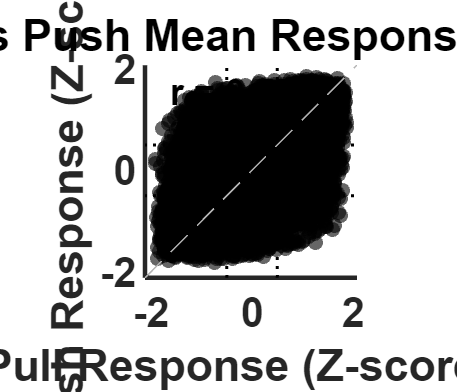

%% 2. レバー応答 (Push vs Pull) の比較と分類プロット

% --- 設定 ---
start_col = 20; % 解析に使用するウィンドウの開始フレーム
end_col = 30;   % 解析に使用するウィンドウの終了フレーム
threshold_low = -0.5; % Z-scoreの下限閾値
threshold_high = 0.5; % Z-scoreの上限閾値

% --- 平均活動の計算 (結合データを使用) ---
% force_act_conc (Pull) と force_act2_conc (Push) を使用
mean_force_act = mean(force_act_conc(:, start_col:end_col), 2);  % Pull response
mean_force_act2 = mean(force_act2_conc(:, start_col:end_col), 2); % Push response

% --- 散布図のプロット ---
figure('Name', 'Lever Push vs Pull Response', 'Color', 'w', 'Position', [100, 100, 700, 600]);
scatter(mean_force_act, mean_force_act2, 25, 'filled', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'none', 'MarkerFaceAlpha', 0.6);

% タイトルと軸ラベル
title('Lever Pull vs Push Mean Response (All Animals)');
xlabel('Pull Response (Z-scored)');
ylabel('Push Response (Z-scored)');

% 軸の調整
all_data = [mean_force_act; mean_force_act2];
min_val = min(all_data) - 0.2;
max_val = max(all_data) + 0.2;
% 見やすくするために範囲を固定したい場合は以下を有効化
% min_val = -2.0; max_val = 2.0; 

xlim([min_val max_val]);
ylim([min_val max_val]);
axis square; % 正方形プロット
hold on;

% 閾値ラインの描画 (グリッド代わり)
plot([threshold_high threshold_high], ylim, 'k:', 'LineWidth', 1); % X = 0.5
plot([threshold_low threshold_low], ylim, 'k:', 'LineWidth', 1);   % X = -0.5
plot(xlim, [threshold_high threshold_high], 'k:', 'LineWidth', 1); % Y = 0.5
plot(xlim, [threshold_low threshold_low], 'k:', 'LineWidth', 1);   % Y = -0.5
plot([min_val max_val], [min_val max_val], 'k--', 'Color', [0.7 0.7 0.7]); % X=Y線

% 相関係数の計算と表示
valid_idx = ~isnan(mean_force_act) & ~isnan(mean_force_act2);
[r, p_val] = corr(mean_force_act(valid_idx), mean_force_act2(valid_idx));
text(min_val + 0.5, max_val - 0.5, sprintf('r = %.3f', r), 'FontSize', 12, 'FontWeight', 'bold');

hold off;
% 保存
saveas(gcf, [output_dir 'AllAnimals_PushPull_Scatter.png']);

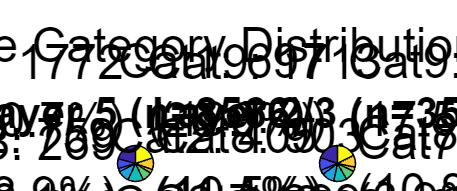



%% 3. 細胞のカテゴリー分類 (1-9)
num_cells = length(mean_force_act);
cell_cats = NaN(num_cells, 1);

for i = 1:num_cells
    val_pull = mean_force_act(i);
    val_push = mean_force_act2(i);
    
    if isnan(val_pull) || isnan(val_push), continue; end
    
    % X軸 (Pull) の判定
    if val_pull < threshold_low
        cat_x = 1; % Suppression
    elseif val_pull > threshold_high
        cat_x = 3; % Activation
    else
        cat_x = 2; % No response
    end
    
    % Y軸 (Push) の判定
    if val_push < threshold_low
        cat_y = 1; % Suppression
    elseif val_push > threshold_high
        cat_y = 3; % Activation
    else
        cat_y = 2; % No response
    end
    
    % 1~9 のカテゴリIDに変換
    % (Row-major order: 1=Low/Low, 2=Mid/Low, 3=High/Low, ...)
    cell_cats(i) = (cat_y - 1) * 3 + cat_x;
end

%% 4. 層ごとの割合プロット (円グラフ)

% 層のID定義 (通常: 1=Layer2/3, 0=Layer5 と仮定)
% pointAreas_conc が結合されている前提
unique_layers = unique(pointAreas_conc(~isnan(pointAreas_conc)));
layer_names = containers.Map({0, 1}, {'Layer 5', 'Layer 2/3'});
colors_cat = parula(9); % カテゴリ用のカラーマップ

figure('Name', 'Category Distribution by Layer', 'Color', 'w', 'Position', [100, 100, 1200, 500]);

for i = 1:length(unique_layers)
    curr_layer = unique_layers(i);
    
    % この層に属する細胞のインデックス
    idx_layer = (pointAreas_conc == curr_layer);
    
    % この層のカテゴリ分布を取得
    cats_in_layer = cell_cats(idx_layer);
    cats_in_layer = cats_in_layer(~isnan(cats_in_layer)); % NaN除去
    
    total_cells = length(cats_in_layer);
    counts = zeros(1, 9);
    for c = 1:9
        counts(c) = sum(cats_in_layer == c);
    end
    pcts = counts / total_cells * 100;
    
    % --- 円グラフの作成 ---
    subplot(1, length(unique_layers), i);
    
    % ラベル作成 (カウントと%を表示)
    labels = arrayfun(@(c) sprintf('Cat%d: %d\n(%.1f%%)', c, counts(c), pcts(c)), 1:9, 'UniformOutput', false);
    
    % 0%のカテゴリはラベルを非表示にする
    labels(pcts == 0) = {''};
    
    p = pie(counts, labels);
    
    % タイトル
    if isKey(layer_names, curr_layer)
        l_name = layer_names(curr_layer);
    else
        l_name = sprintf('Layer ID %d', curr_layer);
    end
    title(sprintf('%s (n=%d)', l_name, total_cells), 'FontSize', 14, 'FontWeight', 'bold');
end

% 凡例の説明図を追加 (別ウィンドウまたは空きスペース)
sgtitle('Lever Response Category Distribution (Pull vs Push)', 'FontSize', 16);

% 保存
saveas(gcf, [output_dir 'AllAnimals_Layer_Category_Pie.png']);


%% 5. カテゴリの意味を出力
fprintf('\n--- Category Definitions ---\n');


--- Category Definitions ---


fprintf('Cat 1: Pull(-), Push(-)\n');

Cat 1: Pull(-), Push(-)


fprintf('Cat 2: Pull(0), Push(-)\n');

Cat 2: Pull(0), Push(-)


fprintf('Cat 3: Pull(+), Push(-)\n');

Cat 3: Pull(+), Push(-)


fprintf('Cat 4: Pull(-), Push(0)\n');

Cat 4: Pull(-), Push(0)


fprintf('Cat 5: Pull(0), Push(0) [Non-responsive]\n');

Cat 5: Pull(0), Push(0) [Non-responsive]


fprintf('Cat 6: Pull(+), Push(0) [Pull Only]\n');

Cat 6: Pull(+), Push(0) [Pull Only]


fprintf('Cat 7: Pull(-), Push(+)\n');

Cat 7: Pull(-), Push(+)


fprintf('Cat 8: Pull(0), Push(+) [Push Only]\n');

Cat 8: Pull(0), Push(+) [Push Only]


fprintf('Cat 9: Pull(+), Push(+) [Both Active]\n');

Cat 9: Pull(+), Push(+) [Both Active]


% caluculate ETA of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    pull_sig_cell_idxs   = cell(0,length(AlinmentTimingCells)+1);
    pull_actss = cell(0,length(AlinmentTimingCells)+1);
    % pull_Is = cell(0,length(AlinmentTimingCells)+1);
    pull_actss_train = cell(0,length(AlinmentTimingCells)+1);
    pull_act_store = cell(length(AlinmentTimingCells),length(Animal));
    for i = 1:length(AlinmentTimingCells)
        for k_animal = 1:length(Animal)
            pull_act      = zeros(size(acc_neural_activity_data_all_sessions{k_animal},2),fps*(before_event+after_event)+1);
            exception_count = 0;
            pull_acts = {};
            pull_idx = AlinmentTimingCells{i};
            for j = 1:size(pull_idx,2)
                if pull_idx(k_animal,j)-fps*before_event<=0 | pull_idx(k_animal,j)+fps*after_event>size(acc_neural_activity_data_all_sessions{k_animal},1)
                    exception_count = exception_count + 1;
                else
                    pull_act = pull_act+transpose(acc_neural_activity_data_all_sessions{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:)); 
                    pull_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:));
                end
            end
            pull_act = pull_act/(size(pull_idx,2)-exception_count);
            pull_acts = reshape(cell2mat(pull_acts),[size(acc_neural_activity_data_all_sessions{k_animal}, 2) size(pull_act,2) size(pull_idx,2)-exception_count]);
            if norm == 1
                pull_act = normalize_rows(pull_act);
            elseif norm ==2
               pull_act = zscore_rows(pull_act); 
            elseif norm ==6
               pull_act = zscore_rows_by_before_pull(pull_act);               
            elseif norm == 4
               if i == 1 | i == 3 | i == 4
                   pull_act_store{i,k_animal} = pull_act;
                   pull_act = zscore_rows(pull_act); 
               elseif i == 2
                   pull_act = zscore_rows_by_diff_matrix(pull_act,pull_act_store{1,k_animal});
               elseif i == 5 | i == 6
                   pull_act = zscore_rows_by_diff_matrix(pull_act,pull_act_store{i-2,k_animal});
               end                         
            elseif norm ==3
                % sig_all, pull_activated-deactivated,
                % pred_activated-deactivated,
                % surprise_activated-deactivated
                sig_cell_idx = zeros(7,size(acc_neural_activity_data_all_sessions{k_animal}, 2));               
                for i_cell = 1:size(acc_neural_activity_data_all_sessions{k_animal}, 2)
                    for l_sig = 1:7
                        if l_sig == 1
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,:,:),3)); 
                        elseif l_sig == 2
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:40,:),3));
                            maxmin_idx = maxmin_idx+20;
                        elseif l_sig == 3
                            [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:40,:),3));
                            maxmin_idx = maxmin_idx+20;
                        elseif l_sig == 4
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,1:20,:),3));
                        elseif l_sig == 5
                            [~,maxmin_idx] = min(mean(pull_acts(i_cell,1:20,:),3)); 
                        elseif l_sig == 6
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:25,:),3));
                            maxmin_idx = maxmin_idx+20;
                        elseif l_sig == 7
                            [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:25,:),3));    
                            maxmin_idx = maxmin_idx+20;
                        end
                        maxmin_pull_acts = pull_acts(i_cell,maxmin_idx,:);
                        [h,p] = ttest2(squeeze(pull_acts(i_cell,:)),squeeze(maxmin_pull_acts),'Vartype','unequal');
                        if h == 1
                            sig_cell_idx(l_sig,i_cell) = 1;
                        else
                            sig_cell_idx(l_sig,i_cell) = 0;
                        end
                    end
                    % pull_sig_cell_idxs{i} = sig_cell_idx;
                end
                pull_act = zscore_rows(pull_act(find(sig_cell_idx(1,:)==1),:));
            elseif norm == 5
                % separete train and test of trial_start_acts
                L = size(pull_acts, 3);
                % 最後の次元に基づいてランダムにインデックスをシャッフル
                indices = randperm(L);        
                % インデックスを2つのグループに分ける
                half_L1 = ceil(L / 2); % (L+1)/2のサイズ
                half_L2 = floor(L / 2); % (L-1)/2のサイズ        
                indices1 = indices(1:half_L1);
                indices2 = indices(half_L1+1:end);         
                % 2つのテンソルに分割
                pull_acts_train = pull_acts(:, :, indices1);
                pull_acts_test  = pull_acts(:, :, indices2);
                % sort with train data
                pull_act_train_raw = mean(pull_acts_train, 3);
                pull_act_test_raw  = mean(pull_acts_test, 3);
                pull_act_train = zscore_rows(pull_act_train_raw);
                pull_act_test  = zscore_rows(pull_act_test_raw);
                pull_act       = zscore_rows(pull_act_test_raw);                
            end

            if k_animal == 1
                pull_act_multi_animals = pull_act;
                if norm == 5
                    pull_act_train_multi_animals = pull_act_train;
                elseif norm == 3
                    sig_cell_idx_multi_animals = sig_cell_idx;
                end
            else
                pull_act_multi_animals = vertcat(pull_act_multi_animals,pull_act);
                if norm == 5
                    pull_act_train_multi_animals = vertcat(pull_act_train_multi_animals,pull_act_train);
                elseif norm == 3
                    sig_cell_idx_multi_animals = horzcat(sig_cell_idx_multi_animals,sig_cell_idx);
                end
            end            
            % [M,pull_I{k_animal}] = max(pull_act,[],2);
            % pull_act = cat(2,pull_I{k_animal},pull_act);
            % pull_act = sortrows(pull_act);
            % pull_act_max_act_times{k_animal} = pull_act(:,1)/10 -2;
            % pull_act(:,1) = [];     
        end
           
        pull_actss{i} = pull_act_multi_animals;
        if norm == 5
            pull_actss_train{i} = pull_act_train_multi_animals;
        elseif norm == 3
            pull_sig_cell_idxs{i} = sig_cell_idx_multi_animals;
        end
        % pull_Is{i} = pull_I;
    end
    % add heavy light combined pull timing
    for k_animal = 1:length(Animal)
        pull_act      = zeros(size(acc_neural_activity_data_all_sessions{k_animal},2),fps*(before_event+after_event)+1);
        exception_count = 0;
        pull_acts = {};
        pull_idx = [AlinmentTimingCells{1},AlinmentTimingCells{2}];
        for j = 1:size(pull_idx,2)
            if pull_idx(k_animal,j)-fps*before_event<=0 | pull_idx(k_animal,j)+fps*after_event>size(acc_neural_activity_data_all_sessions{k_animal},1)
                exception_count = exception_count + 1;
            else
                pull_act = pull_act+transpose(acc_neural_activity_data_all_sessions{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:)); 
                pull_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:));
            end
        end
        pull_act = pull_act/(size(pull_idx,2)-exception_count);
        pull_acts = reshape(cell2mat(pull_acts),[size(acc_neural_activity_data_all_sessions{k_animal}, 2) size(pull_act,2) size(pull_idx,2)-exception_count]);
        if norm == 1
            pull_act = normalize_rows(pull_act);
        elseif norm ==2 || norm == 4
           pull_act = zscore_rows(pull_act); 
        elseif norm ==6
           pull_act = zscore_rows_by_before_pull(pull_act);           
        elseif norm ==3
            % sig_all, pull_activated-deactivated,
            % pred_activated-deactivated,
            % surprise_activated-deactivated
            sig_cell_idx = zeros(7,size(acc_neural_activity_data_all_sessions{k_animal}, 2));               
            for i_cell = 1:size(acc_neural_activity_data_all_sessions{k_animal}, 2)
                for l_sig = 1:7
                    if l_sig == 1
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,:,:),3)); 
                    elseif l_sig == 2
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:40,:),3));
                        maxmin_idx = maxmin_idx+20;
                    elseif l_sig == 3
                        [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:40,:),3));
                        maxmin_idx = maxmin_idx+20;
                    elseif l_sig == 4
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,1:20,:),3));
                    elseif l_sig == 5
                        [~,maxmin_idx] = min(mean(pull_acts(i_cell,1:20,:),3)); 
                    elseif l_sig == 6
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:25,:),3));
                        maxmin_idx = maxmin_idx+20;
                    elseif l_sig == 7
                        [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:25,:),3));    
                        maxmin_idx = maxmin_idx+20;
                    end
                    maxmin_pull_acts = pull_acts(i_cell,maxmin_idx,:);
                    [h,p] = ttest2(squeeze(pull_acts(i_cell,:)),squeeze(maxmin_pull_acts),'Vartype','unequal');
                    if h == 1
                        sig_cell_idx(l_sig,i_cell) = 1;
                    else
                        sig_cell_idx(l_sig,i_cell) = 0;
                    end
                end
                % pull_sig_cell_idxs{i+1} = sig_cell_idx;
            end
            pull_act = zscore_rows(pull_act(find(sig_cell_idx(1,:)==1),:));            
        elseif norm == 5
            % separete train and test of trial_start_acts
            L = size(pull_acts, 3);
            % 最後の次元に基づいてランダムにインデックスをシャッフル
            indices = randperm(L);        
            % インデックスを2つのグループに分ける
            half_L1 = ceil(L / 2); % (L+1)/2のサイズ
            half_L2 = floor(L / 2); % (L-1)/2のサイズ        
            indices1 = indices(1:half_L1);
            indices2 = indices(half_L1+1:end);         
            % 2つのテンソルに分割
            pull_acts_train = pull_acts(:, :, indices1);
            pull_acts_test  = pull_acts(:, :, indices2);
            % sort with train data
            pull_act_train_raw = mean(pull_acts_train, 3);
            pull_act_test_raw  = mean(pull_acts_test, 3);
            pull_act_train = zscore_rows(pull_act_train_raw);
            pull_act_test  = zscore_rows(pull_act_test_raw);
            pull_act       = zscore_rows(pull_act_test_raw);             
        end

        if k_animal == 1
            pull_act_multi_animals = pull_act;
            if norm == 5
                pull_act_train_multi_animals = pull_act_train;
            elseif norm == 3
                sig_cell_idx_multi_animals = sig_cell_idx;                
            end            
        else
            pull_act_multi_animals = vertcat(pull_act_multi_animals,pull_act);
            if norm == 5
                pull_act_train_multi_animals = vertcat(pull_act_train_multi_animals,pull_act_train);
            elseif norm == 3
                sig_cell_idx_multi_animals = horzcat(sig_cell_idx_multi_animals,sig_cell_idx);                
            end            
        end            
        % [M,pull_I{k_animal}] = max(pull_act,[],2);
        % pull_act = cat(2,pull_I{k_animal},pull_act);
        % pull_act = sortrows(pull_act);
        % pull_act_max_act_times{k_animal} = pull_act(:,1)/10 -2;
        % pull_act(:,1) = [];
    end
    pull_actss{i+1} = pull_act_multi_animals;
    % pull_Is{i+1} = pull_I;
    if norm == 5
        pull_actss_train{i+1} = pull_act_train_multi_animals;
    elseif norm == 3
        pull_sig_cell_idxs{i+1} = sig_cell_idx_multi_animals;        
    end    
end

% write eta code by categrizing neurons by layers

if strcmp(categorize, 'layer') == 1
    % align concatenated eta neural activities
    [M,trial_start_i] = max(trial_start_act_conc,[],2);
    [M,trial_end_i] = max(trial_end_act_conc,[],2);  
    [M,position_i] = max(position_act_conc,[],2);
    [M,force_i] = max(force_act_conc,[],2);
    [M,force2_i] = max(force_act2_conc,[],2);
    [M,reward_i] = max(reward_act_conc,[],2);

    if norm==3
        trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc(find(sig_cell_idxs_conc{1} == 1)) ,trial_start_act_conc);
        trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc(find(sig_cell_idxs_conc{2} == 1)) ,trial_end_act_conc);
        position_act_conc = cat(2, position_i,pointAreas_conc(find(sig_cell_idxs_conc{3} == 1)) ,position_act_conc);
        force_act_conc = cat(2, force_i,pointAreas_conc(find(sig_cell_idxs_conc{4} == 1)) ,force_act_conc);
        force_act2_conc = cat(2, force2_i,pointAreas_conc(find(sig_cell_idxs_conc{6} == 1)) ,force_act2_conc);
        reward_act_conc = cat(2, reward_i,pointAreas_conc(find(sig_cell_idxs_conc{5} == 1)) ,reward_act_conc);
    else
        trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc ,trial_start_act_conc);
        trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc ,trial_end_act_conc);
        position_act_conc = cat(2, position_i,pointAreas_conc ,position_act_conc);
        force_act_conc = cat(2, force_i,pointAreas_conc ,force_act_conc);
        force_act2_conc = cat(2, force2_i,pointAreas_conc ,force_act2_conc);
        reward_act_conc = cat(2, reward_i,pointAreas_conc ,reward_act_conc);
    end

    trial_start_act_conc =   sortrows(trial_start_act_conc);
    trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startAreas = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];

    trial_end_act_conc =   sortrows(trial_end_act_conc);
    trial_end_act_max_act_time_conc = trial_end_act_conc(:,1)/10 -2;
    endAreas = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];  

    position_act_conc =   sortrows(position_act_conc);
    position_act_max_act_time_conc = position_act_conc(:,1)/10 -2;
    positionAreas = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];    

    force_act_conc =   sortrows(force_act_conc);
    force_act_max_act_time_conc = force_act_conc(:,1)/10 -2;
    forceAreas = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];    

    force_act2_conc =   sortrows(force_act2_conc);
    force_act2_max_act_time_conc = force_act2_conc(:,1)/10 -2;
    forceAreas2 = force_act2_conc(:,2);
    force_act2_conc(:,1:2) = [];        

    reward_act_conc =   sortrows(reward_act_conc);
    reward_act_max_act_time_conc = reward_act_conc(:,1)/10 -2;
    rewardAreas = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];    

    % specify layer specific activity
    trial_start_act_layer23_conc = trial_start_act_conc(find(startAreas == 1),:);
    trial_start_act_layer5_conc  = trial_start_act_conc(find(startAreas == 0),:);
    trial_end_act_layer23_conc = trial_end_act_conc(find(endAreas == 1),:);
    trial_end_act_layer5_conc  = trial_end_act_conc(find(endAreas == 0),:);
    position_act_layer23_conc = position_act_conc(find(positionAreas == 1),:);
    position_act_layer5_conc  = position_act_conc(find(positionAreas == 0),:);
    force_act_layer23_conc = force_act_conc(find(forceAreas == 1),:);
    force_act_layer5_conc  = force_act_conc(find(forceAreas == 0),:);
    force_act2_layer23_conc = force_act2_conc(find(forceAreas2 == 1),:);
    force_act2_layer5_conc  = force_act2_conc(find(forceAreas2 == 0),:);    
    reward_act_layer23_conc = reward_act_conc(find(rewardAreas == 1),:);
    reward_act_layer5_conc  = reward_act_conc(find(rewardAreas == 0),:);
end

if strcmp(categorize, 'layer') == 1 & norm == 5
    % align concatenated eta neural activities
    % pointAreas_train_conc = pointAreas_conc(find(train_test_indices==1));
    % pointAreas_test_conc  = pointAreas_conc(find(train_test_indices==2));

    [M,trial_start_i] = max(trial_start_act_train_conc,[],2);
    trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc ,trial_start_act_train_conc, trial_start_act_test_conc);
    trial_start_act_conc =   sortrows(trial_start_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startAreas_train = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];
    trial_len = size(trial_start_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    trial_start_act_test_conc  = trial_start_act_conc(:,trial_len+1:size(trial_start_act_conc,2));  
    trial_start_act_conc = trial_start_act_test_conc; 

    [M,trial_end_i] = max(trial_end_act_train_conc,[],2);
    trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc ,trial_end_act_train_conc, trial_end_act_test_conc);
    trial_end_act_conc =   sortrows(trial_end_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    endAreas_train = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];
    trial_len = size(trial_end_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    trial_end_act_test_conc  = trial_end_act_conc(:,trial_len+1:size(trial_end_act_conc,2));  
    trial_end_act_conc = trial_end_act_test_conc;    

    [M,position_i] = max(position_act_train_conc,[],2);
    position_act_conc = cat(2, position_i,pointAreas_conc ,position_act_train_conc, position_act_test_conc);
    position_act_conc =   sortrows(position_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    positionAreas_train = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];
    trial_len = size(position_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    position_act_test_conc  = position_act_conc(:,trial_len+1:size(position_act_conc,2));  
    position_act_conc = position_act_test_conc; 

    [M,force_i] = max(force_act_train_conc,[],2);
    force_act_conc = cat(2, force_i,pointAreas_conc ,force_act_train_conc, force_act_test_conc);
    force_act_conc =   sortrows(force_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    forceAreas_train = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];
    trial_len = size(force_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    force_act_test_conc  = force_act_conc(:,trial_len+1:size(force_act_conc,2));  
    force_act_conc = force_act_test_conc;   

    [M,force2_i] = max(force_act2_train_conc,[],2);
    force_act2_conc = cat(2, force2_i,pointAreas_conc ,force_act2_train_conc, force_act2_test_conc);
    force_act2_conc =   sortrows(force_act2_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    forceAreas2_train = force_act2_conc(:,2);
    force_act2_conc(:,1:2) = [];
    trial_len = size(force_act2_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    force_act2_test_conc  = force_act2_conc(:,trial_len+1:size(force_act2_conc,2));  
    force_act2_conc = force_act2_test_conc;     

    [M,reward_i] = max(reward_act_train_conc,[],2);
    reward_act_conc = cat(2, reward_i,pointAreas_conc ,reward_act_train_conc, reward_act_test_conc);
    reward_act_conc =   sortrows(reward_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    rewardAreas_train = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];
    trial_len = size(reward_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    reward_act_test_conc  = reward_act_conc(:,trial_len+1:size(reward_act_conc,2));  
    reward_act_conc = reward_act_test_conc;      

    % specify layer specific activity
    trial_start_act_layer23_conc = trial_start_act_test_conc(find(startAreas_train == 1),:);
    trial_start_act_layer5_conc  = trial_start_act_test_conc(find(startAreas_train == 0),:);    
    trial_end_act_layer23_conc   = trial_end_act_test_conc(find(endAreas_train == 1),:);
    trial_end_act_layer5_conc    = trial_end_act_test_conc(find(endAreas_train == 0),:);  
    position_act_layer23_conc    = position_act_test_conc(find(positionAreas_train == 1),:);
    position_act_layer5_conc     = position_act_test_conc(find(positionAreas_train == 0),:);    
    force_act_layer23_conc       = force_act_test_conc(find(forceAreas_train == 1),:);
    force_act_layer5_conc        = force_act_test_conc(find(forceAreas_train == 0),:);  
    force_act2_layer23_conc       = force_act2_test_conc(find(forceAreas2_train == 1),:);
    force_act2_layer5_conc        = force_act2_test_conc(find(forceAreas2_train == 0),:); 
    reward_act_layer23_conc      = reward_act_test_conc(find(rewardAreas_train == 1),:);
    reward_act_layer5_conc       = reward_act_test_conc(find(rewardAreas_train == 0),:);      

    % zscore and return only test data
    % trial_start_act_raw = trial_start_act_test_raw;
    % trial_start_act = zscore_rows(trial_start_act_test);
end

% write eta code by categrizing neurons by layers for Kota (pull) timing alignment
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    num_conditions = length(AlinmentTimingCells)+1;
    pull_act_layer23_cells   = cell(0,num_conditions);
    pull_act_layer5_cells    = cell(0,num_conditions);
    pullAreass   = cell(0,num_conditions);
    pull_actss_ordered = cell(0,num_conditions);
    if norm == 5
        for i = 1:num_conditions
            pull_act_test_multi_animals = pull_actss{i};
            pull_act_train_multi_animals = pull_actss_train{i};            
        % align concatenated eta neural activities
            [M,pull_i] = max(pull_act_train_multi_animals,[],2);
            pull_act_multi_animals = cat(2, pull_i,pointAreas_conc ,pull_act_train_multi_animals,pull_act_test_multi_animals);
            pull_act_multi_animals = sortrows(pull_act_multi_animals);
            % pull_act_max_act_time_multi_animals = pull_act_multi_animals(:,1)/10 -2;
            pullAreas = pull_act_multi_animals(:,2);
            pull_act_multi_animals(:,1:2) = [];
            trial_len = size(pull_act_train_multi_animals,2);
            pull_act_multi_animals_test = pull_act_multi_animals(:,trial_len+1:size(pull_act_multi_animals,2));
            pull_actss_ordered{i} = pull_act_multi_animals_test;
    
            pull_act_layer23_cells{i} = pull_act_multi_animals_test(find(pullAreas == 1),:); 
            pull_act_layer5_cells{i}  = pull_act_multi_animals_test(find(pullAreas == 0),:);
            pullAreass{i} = pullAreas;
        end
    else
        for i = 1:num_conditions
            pull_act_multi_animals = pull_actss{i};
        % align concatenated eta neural activities
            [M,pull_i] = max(pull_act_multi_animals,[],2);

            if norm==3
                pull_act_multi_animals = cat(2, pull_i,pointAreas_conc(find(pull_sig_cell_idxs{i}(1,:) == 1)) ,pull_act_multi_animals);
            else
                pull_act_multi_animals = cat(2, pull_i,pointAreas_conc ,pull_act_multi_animals);
            end

            pull_act_multi_animals = sortrows(pull_act_multi_animals);
            % pull_act_max_act_time_multi_animals = pull_act_multi_animals(:,1)/10 -2;
            pullAreas = pull_act_multi_animals(:,2);
            pull_act_multi_animals(:,1:2) = [];
            pull_actss_ordered{i} = pull_act_multi_animals;
    
            pull_act_layer23_cells{i} = pull_act_multi_animals(find(pullAreas == 1),:); %% TODO: need to modify
            pull_act_layer5_cells{i}  = pull_act_multi_animals(find(pullAreas == 0),:);
            pullAreass{i} = pullAreas;
        end
    end
end

% write eta code with depth

if strcmp(categorize, 'depth') == 1
    % align concatenated eta neural activities
    [M,trial_start_i] = max(trial_start_act_conc,[],2);
    trial_start_act_conc = cat(2, trial_start_i,depth_conc ,trial_start_act_conc);
    trial_start_act_conc =   sortrows(trial_start_act_conc);
    trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startDepth = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];

    [M,trial_end_i] = max(trial_end_act_conc,[],2);
    trial_end_act_conc = cat(2, trial_end_i,depth_conc ,trial_end_act_conc);
    trial_end_act_conc =   sortrows(trial_end_act_conc);
    trial_end_act_max_act_time_conc = trial_end_act_conc(:,1)/10 -2;
    endDepth = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];  

    [M,position_i] = max(position_act_conc,[],2);
    position_act_conc = cat(2, position_i,depth_conc ,position_act_conc);
    position_act_conc =   sortrows(position_act_conc);
    position_act_max_act_time_conc = position_act_conc(:,1)/10 -2;
    posDepth = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];    

    [M,force_i] = max(force_act_conc,[],2);
    force_act_conc = cat(2, force_i,depth_conc ,force_act_conc);
    force_act_conc =   sortrows(force_act_conc);
    force_act_max_act_time_conc = force_act_conc(:,1)/10 -2;
    forceDepth = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];    

    [M,force2_i] = max(force_act2_conc,[],2);
    force_act2_conc = cat(2, force2_i,depth_conc ,force_act2_conc);
    force_act2_conc =   sortrows(force_act2_conc);
    force_act2_max_act_time_conc = force_act2_conc(:,1)/10 -2;
    forceDepth2 = force_act2_conc(:,2);
    force_act2_conc(:,1:2) = [];        

    [M,reward_i] = max(reward_act_conc,[],2);
    reward_act_conc = cat(2, reward_i,depth_conc ,reward_act_conc);
    reward_act_conc =   sortrows(reward_act_conc);
    reward_act_max_act_time_conc = reward_act_conc(:,1)/10 -2;
    rewardDepth = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];    
end

% write eta code by categrizing neurons by layers for Kota (pull) timing alignment
if strcmp(categorize, 'depth') == 1 & Kota_alignment == 1
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
    pullDepths   = cell(0,length(AlinmentTimingCells));
    for i = 1:length(AlinmentTimingCells)
        pull_act_multi_animals = pull_actss{i};
    % align concatenated eta neural activities
        [M,pull_i] = max(pull_act_multi_animals,[],2);
        pull_act_multi_animals = cat(2, pull_i,depth_conc ,pull_act_multi_animals);
        pull_act_multi_animals = sortrows(pull_act_multi_animals);
        pull_act_max_act_time_multi_animals = pull_act_multi_animals(:,1)/10 -2;
        pullDepth = pull_act_multi_animals(:,2);
        pull_act_multi_animals(:,1:2) = [];
        % 
        % pull_act_layer23_cells{i} = pull_actss{i}(:,find(pullAreas == 1),:); %% TODO: need to modify
        % pull_act_layer5_cells{i}  = pull_actss{i}(:,find(pullAreas == 0),:);
        pullDepths{i} = pullDepth;
    end
end

% plot neural activity heatmap
if norm == 1
    climit = [0 1];
elseif norm == 2 | norm == 3 | norm == 4 | norm == 5 
    climit = [-2 2];
elseif norm == 6
    climit = [-4 4];
else
    climit = [0 50];
end
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_start_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.0444    0.9115    0.9429    0.8725    0.8802    0.7845    0.7454    0.8225    0.8081    0.7812    0.8005    0.6773    0.5359    0.6078    0.3827    0.2780    0.1143   -0.0230   -0.1246   -0.2468   -0.4952   -0.8406   -1.3174   -1.6652   -1.8595   -1.7853   -1.7753   -1.8723   -1.7813   -1.6502   -1.6635   -1.6999   -1.5338   -1.4486   -1.2835   -1.0855   -0.8758   -0.7019   -0.4493   -0.1870   -0.0741    0.0803    0.3103    0.5424    0.6661    0.7855    0.8320    0.8629    0.9628    0.9574
    1.0581    0.9754    0.9230    0.8642    0.7858    0.6785    0.7240    0.5796    0.5303    0.3933    0.2796    0.2525    0.1211    0.0656   -0.0803   -0.1932   -0.4016   -0.5195   -0.6926   -0.9973   -1.1419   -1.5540   -1.9953   -2.3159   -2.1842   -2.1194   -1.9720   -1.7864   -1.5631   -1.4190   -1.3277   -1.0041   -0.8322   -0.5575   -0.5100   -0.2917   -0.1227    0.1090    0.2490    0.4258    0.4352    0.4550    0.6392    0.6646    0.7150    0.7000    0.7861    0.7769    0.7420 

    imagesc(-before_event:0.1:after_event,1:size(trial_start_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_start_eta_activity_heatmap.png'];
filename = [output_dir 'trial_start_eta_activity_heatmap.png'];
saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_end_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     0.8217    0.7613    0.6973    0.5335    0.5588    0.3254    0.3015    0.4249    0.5148    0.4526    0.6722    0.5928    0.6780    0.6347    0.5537    0.4451    0.4400    0.6803    0.5983    0.4297    0.4421    0.1941   -0.4405   -1.1385   -1.5473   -1.9251   -2.2660   -2.4339   -2.3692   -2.2657   -2.2834   -1.9058   -1.6246   -1.5454   -1.2878   -0.6556   -0.5746   -0.0136    0.1052    0.2487    0.3484    0.4010    0.6209    0.7578    0.7292    0.8084    0.8040    0.7244    0.6066    0.5899
    0.9907    0.6623    0.7184    0.5601    0.7998    0.9584    0.8775    0.7692    0.7734    0.7702    0.6244    0.7297    0.5200    0.5153    0.5137    0.7094    0.6975    0.8442    0.6212    0.4589    0.2756   -0.3829   -0.8744   -1.6328   -2.1877   -2.6383   -2.3741   -2.3208   -2.3263   -2.0221   -1.5681   -1.6885   -1.0408   -1.0794   -0.5940   -0.3111   -0.1550    0.1973    0.2363    0.3803    0.1551    0.1818    0.0304    0.0153    0.0466    0.0336   -0.0462    0.1950   -0.0011 

    imagesc(-before_event:0.1:after_event,1:size(trial_end_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_end_eta_activity_heatmap.png'];
filename = [output_dir 'trial_end_eta_activity_heatmap.png'];
saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = position_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.0946    0.4120   -0.4160   -1.0436   -1.8686   -2.2817   -2.5853   -2.4043   -2.4106   -2.2972   -1.7653   -1.4090   -1.1872   -1.0513   -0.7191   -0.3601   -0.1514    0.0666    0.1860    0.4538    0.6038    0.6060    0.5690    0.3601    0.0186   -0.1547   -0.3594   -0.2946   -0.4325   -0.2959   -0.2811   -0.0923    0.0576    0.1849    0.2293    0.4064    0.4332    0.7406    0.8386    1.0804    1.0548    1.0655    0.8327    0.8009    0.7579    0.8421    0.8911    0.7130    0.8034    0.8048
    1.1074    0.9677    0.7698    0.5111    0.2157    0.0094   -0.3149   -0.4264   -0.6160   -0.7836   -0.9613   -1.1105   -1.2519   -1.3555   -1.4761   -1.6412   -1.6314   -1.6472   -1.8198   -1.9021   -2.0295   -2.0669   -1.8704   -1.5012   -1.1432   -0.6962   -0.3034    0.0819    0.3364    0.5705    0.8103    0.9223    1.0787    0.9759    1.0102    0.9800    0.9537    0.9430    0.8737    0.7936    0.7265    0.6532    0.5662    0.5518    0.5605    0.5536    0.6012    0.5845    0.6501 

    imagesc(-before_event:0.1:after_event,1:size(position_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_position_eta_activity_heatmap.png'];
filename = [output_dir 'position_eta_activity_heatmap.png'];
saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = force_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.0605    0.8262    0.5606    0.3951    0.4397    0.6929    0.2764    0.3397    0.7246    0.4215    0.3368    0.2394    0.2240    0.2731    0.1230   -0.0343   -0.2589   -0.2145   -0.6520   -0.5588   -1.1256   -1.5290   -2.1515   -2.5863   -2.7798   -2.8002   -2.2727   -2.3890   -1.1450   -1.1455   -0.6767   -0.2690    0.0002    0.2837    0.4610    0.6025    0.7791    0.8468    0.7938    0.6673    1.0564    0.3788    0.4429    0.9049    0.7002    0.5021    0.5714    0.4757    0.5927    0.8731
    1.0743    1.0643    0.9556    1.0341    1.0497    0.8867    0.9088    0.7315    0.5568    0.3877    0.3198    0.0702    0.1064   -0.1074   -0.4311   -0.5865   -0.7188   -0.9239   -1.1675   -1.4099   -1.8920   -2.1714   -2.0519   -1.8262   -1.7102   -1.6041   -1.5764   -1.3761   -1.3044   -1.2004   -1.0416   -0.8529   -0.7637   -0.4496   -0.4316   -0.2021   -0.1989   -0.1190   -0.0409    0.0051    0.2432    0.4535    0.5166    0.5440    0.4524    0.6670    0.7807    0.8254    0.8699 

    imagesc(-before_event:0.1:after_event,1:size(force_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_force_eta_activity_heatmap.png'];
filename = [output_dir 'force_eta_activity_heatmap.png'];
saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = force_act2_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     0.9402    0.8652    0.8223    0.9209    0.8106    0.8870    0.6235    0.5906    0.3884    0.5589    0.3160    0.0891    0.3899    0.1540   -0.0339    0.1242    0.1672    0.6244    0.4770    0.3578    0.2441    0.5042    0.1720    0.2208   -0.2909   -0.8131   -1.5225   -2.0188   -2.1413   -2.4963   -2.4629   -2.5287   -2.7563   -2.1593   -1.4238   -1.0421   -0.6146   -0.2513    0.0663    0.3175    0.2719    0.5523    0.4800    0.7765    0.8841    0.3058    0.6924    0.5689    0.5498    0.5493
    1.0229    0.9731    0.8682    0.8118    0.8003    0.7905    0.6475    0.6547    0.6590    0.6334    0.6228    0.4987    0.4619    0.5213    0.5032    0.4737    0.4324    0.4304    0.3618    0.3004    0.1431    0.0176   -0.2427   -0.7851   -1.1999   -1.5336   -1.7543   -1.9754   -2.1427   -2.1831   -2.1747   -2.0354   -1.8447   -1.6838   -1.4516   -1.2203   -0.9921   -0.7226   -0.5937   -0.3332   -0.1936   -0.0885    0.0143    0.1407    0.2597    0.3480    0.4329    0.5069    0.5626 

    imagesc(-before_event:0.1:after_event,1:size(force_act2_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_force_eta_activity_heatmap.png'];
filename = [output_dir 'minus_force_eta_activity_heatmap.png'];
saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = reward_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     0.9758    0.7921    0.9324    0.8636    0.7041    0.7570    0.7135    0.7138    0.7333    0.6465    0.7519    0.6467    0.5984    0.6366    0.6189    0.6754    0.6016    0.5725    0.5329    0.3073    0.0975   -0.3112   -0.5576   -1.0470   -1.4942   -2.0531   -2.5010   -2.6210   -2.6361   -2.5413   -2.1566   -1.5358   -1.1492   -0.7185   -0.6783   -0.2783   -0.2045   -0.0765   -0.0234    0.0024    0.0423    0.0195    0.0022   -0.0546    0.0729    0.0326   -0.0209    0.0899    0.2402    0.3569
    1.0128    1.0001    0.9666    0.9653    0.9340    0.9822    0.9376    0.9134    0.9103    0.8632    0.7800    0.7948    0.7383    0.6300    0.5973    0.4800    0.4002    0.4961    0.4879    0.5417    0.6854    0.6811    0.5853    0.2660   -0.0399   -0.2930   -0.6143   -0.8960   -1.1612   -1.2994   -1.4565   -1.4894   -1.5812   -1.5953   -1.6736   -1.7406   -1.7675   -1.7670   -1.7707   -1.7278   -1.5535   -1.3038   -1.0328   -0.8926   -0.6439   -0.4974   -0.2864   -0.0188    0.2210 

    imagesc(-before_event:0.1:after_event,1:size(reward_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_reward_eta_activity_heatmap.png'];
filename = [output_dir 'reward_eta_activity_heatmap.png'];
saveas(gcf,filename);
close all;

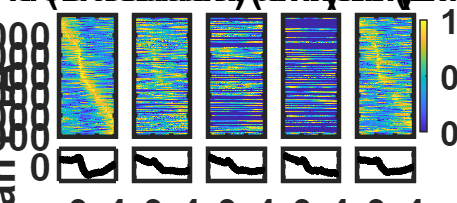

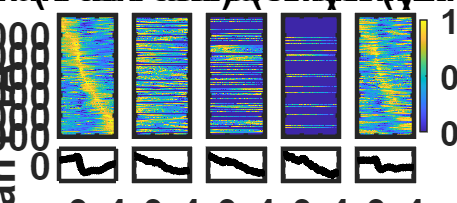

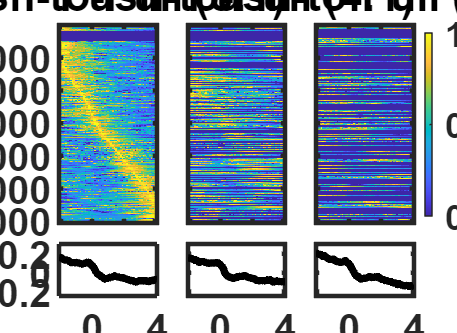

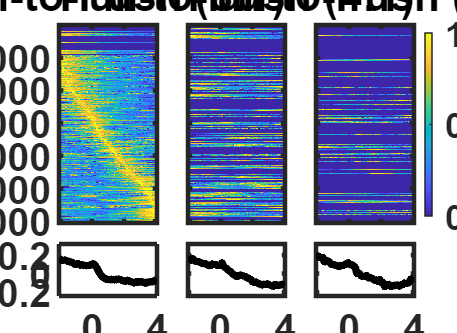

if unified2604
    % =========================================================================
    % ETA 比較プロット (平均波形付き・論文/スライド用フォーマット)
    % =========================================================================
    
    % グローバルスタイル設定
    set(0, 'DefaultAxesFontSize', 16);
    set(0, 'DefaultTextFontSize', 16);
    set(0, 'DefaultAxesFontWeight', 'bold');
    set(0, 'DefaultAxesLineWidth', 1.5);
    
    if norm == 1
        climit = [0 1];
    elseif ismember(norm, [2, 3, 4, 5])
        climit = [-2 2];
    elseif norm == 6
        climit = [-4 4];
    else
        climit = [0 50];
    end
    
    time_axis = -before_event:0.1:after_event;
    
    %% 1. Push 5パネル比較
    figure('Position', [50, 100, 1800, 800], 'Color', 'w'); % 折れ線グラフ追加のため縦幅を少し拡大
    t_title_push = {'Push (Success)', 'Push-to-Pull (8:1)', 'Push-to-Pull (4:1)', 'Push-to-Pull (2:1)', 'Push (Fail)'};
    push_data = {push_success_conc, push_p2p_8_1_conc, push_p2p_4_1_conc, push_p2p_2_1_conc, push_fail_conc};
    
    if norm == 5
        [~, max_idx_push] = max(push_success_train_conc, [], 2);
    else
        [~, max_idx_push] = max(push_data{1}, [], 2);
    end
    [~, sort_order_push] = sort(max_idx_push);
    
    % 全パネル共通の平均波形Y軸スケールを計算
    push_means = cellfun(@(x) mean(x, 1, 'omitnan'), push_data, 'UniformOutput', false);
    tmp_push = cell2mat(push_means');
    ylim_line_push = [min(tmp_push(:)) - 0.1, max(tmp_push(:)) + 0.1];
    if isnan(ylim_line_push(1)) || ylim_line_push(1) >= ylim_line_push(2)
        ylim_line_push = [-1, 1]; % 万が一データが空の場合のエラー回避
    end

    for i = 1:5
        % --- ヒートマップ (上3/4) ---
        subplot(4, 5, [i, i+5, i+10]);
        sorted_image = push_data{i}(sort_order_push, :);
        h = imagesc(time_axis, 1:size(sorted_image, 1), sorted_image, climit);
        set(gca, 'Color', 'w');
        
        title(t_title_push{i}, 'FontSize', 18, 'FontWeight', 'bold');
        set(gca, 'XTickLabel', []); % ヒートマップのX軸ラベルを消して下に繋げる
        
        if i == 1
            ylabel('Cell', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on; axis tight;
        
        % --- 平均波形 (下1/4) ---
        subplot(4, 5, i+15);
        plot(time_axis, push_means{i}, 'k', 'LineWidth', 2.5);
        set(gca, 'Color', 'w');
        xlim([time_axis(1) time_axis(end)]);
        ylim(ylim_line_push); % スケール統一
        xlabel('Time (sec)', 'FontSize', 16);
        
        if i == 1
            ylabel('Mean ETA', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on;
    end
    
    % カラーバーの位置調整 (ヒートマップの高さに合わせる)
    cb1 = colorbar;
    cb1.Position = [0.92 0.35 0.015 0.55]; 
    cb1.Label.String = 'Activity (Z-score)';
    cb1.Label.FontSize = 16;
    saveas(gcf, [output_dir 'Push_5panels_heatmap_with_mean_success.png']);
    
    
    %% 2. Pull 5パネル比較
    figure('Position', [50, 300, 1800, 800], 'Color', 'w');
    t_title_pull = {'Pull (Success)', 'Pull-to-Push (8:1)', 'Pull-to-Push (4:1)', 'Pull-to-Push (2:1)', 'Pull (Fail)'};
    pull_data = {pull_success_conc, pull_p2push_8_1_conc, pull_p2push_4_1_conc, pull_p2push_2_1_conc, pull_fail_conc};
    
    if norm == 5
        [~, max_idx_pull] = max(pull_success_train_conc, [], 2);
    else
        [~, max_idx_pull] = max(pull_data{1}, [], 2);
    end
    [~, sort_order_pull] = sort(max_idx_pull);
    
    pull_means = cellfun(@(x) mean(x, 1, 'omitnan'), pull_data, 'UniformOutput', false);
    tmp_pull = cell2mat(pull_means');
    ylim_line_pull = [min(tmp_pull(:)) - 0.1, max(tmp_pull(:)) + 0.1];
    if isnan(ylim_line_pull(1)) || ylim_line_pull(1) >= ylim_line_pull(2)
        ylim_line_pull = [-1, 1];
    end

    for i = 1:5
        subplot(4, 5, [i, i+5, i+10]);
        sorted_image = pull_data{i}(sort_order_pull, :);
        h = imagesc(time_axis, 1:size(sorted_image, 1), sorted_image, climit);
        set(gca, 'Color', 'w');
        
        title(t_title_pull{i}, 'FontSize', 18, 'FontWeight', 'bold');
        set(gca, 'XTickLabel', []);
        
        if i == 1
            ylabel('Cell', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on; axis tight;
        
        subplot(4, 5, i+15);
        plot(time_axis, pull_means{i}, 'k', 'LineWidth', 2.5);
        set(gca, 'Color', 'w');
        xlim([time_axis(1) time_axis(end)]);
        ylim(ylim_line_pull);
        xlabel('Time (sec)', 'FontSize', 16);
        
        if i == 1
            ylabel('Mean ETA', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on;
    end
    
    cb2 = colorbar;
    cb2.Position = [0.92 0.35 0.015 0.55]; 
    cb2.Label.String = 'Activity (Z-score)';
    cb2.Label.FontSize = 16;
    saveas(gcf, [output_dir 'Pull_5panels_heatmap_with_mean_success.png']);


    %% 3. Push-to-Pull (最後のPull基準) 3パネル
    figure('Position', [100, 100, 1100, 800], 'Color', 'w');
    t_title_p2p = {'Push-to-Pull (8:1)', 'Push-to-Pull (4:1)', 'Push-to-Pull (2:1)'};
    data_p2p = {p2p_pull_8_1_conc, p2p_pull_4_1_conc, p2p_pull_2_1_conc};
    
    if norm == 5
        [~, max_idx_p2p] = max(p2p_pull_8_1_train_conc, [], 2);
    else
        [~, max_idx_p2p] = max(data_p2p{1}, [], 2);
    end
    [~, sort_order_p2p] = sort(max_idx_p2p);
    
    p2p_means = cellfun(@(x) mean(x, 1, 'omitnan'), data_p2p, 'UniformOutput', false);
    tmp_p2p = cell2mat(p2p_means');
    ylim_line_p2p = [min(tmp_p2p(:)) - 0.1, max(tmp_p2p(:)) + 0.1];
    if isnan(ylim_line_p2p(1)) || ylim_line_p2p(1) >= ylim_line_p2p(2)
        ylim_line_p2p = [-1, 1];
    end

    for i = 1:3
        subplot(4, 3, [i, i+3, i+6]);
        sorted_image = data_p2p{i}(sort_order_p2p, :);
        h = imagesc(time_axis, 1:size(sorted_image, 1), sorted_image, climit);
        set(gca, 'Color', 'w');
        
        title(t_title_p2p{i}, 'FontSize', 18, 'FontWeight', 'bold');
        set(gca, 'XTickLabel', []);
        
        if i == 1
            ylabel('Cell (Sorted by 8:1)', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on; axis tight;
        
        subplot(4, 3, i+9);
        plot(time_axis, p2p_means{i}, 'k', 'LineWidth', 2.5);
        set(gca, 'Color', 'w');
        xlim([time_axis(1) time_axis(end)]);
        ylim(ylim_line_p2p);
        xlabel('Time (sec)', 'FontSize', 16);
        
        if i == 1
            ylabel('Mean ETA', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on;
    end
    
    cb3 = colorbar;
    cb3.Position = [0.93 0.35 0.015 0.55]; 
    cb3.Label.String = 'Activity (Z-score)';
    saveas(gcf, [output_dir 'Push_to_Pull_LastPull_3panels_with_mean.png']);
    
    
    %% 4. Pull-to-Push (最後のPush基準) 3パネル
    figure('Position', [100, 300, 1100, 800], 'Color', 'w');
    t_title_p2push = {'Pull-to-Push (8:1)', 'Pull-to-Push (4:1)', 'Pull-to-Push (2:1)'};
    data_p2push = {p2push_push_8_1_conc, p2push_push_4_1_conc, p2push_push_2_1_conc};
    
    if norm == 5
        [~, max_idx_p2push] = max(p2push_push_8_1_train_conc, [], 2);
    else
        [~, max_idx_p2push] = max(data_p2push{1}, [], 2);
    end
    [~, sort_order_p2push] = sort(max_idx_p2push);
    
    p2push_means = cellfun(@(x) mean(x, 1, 'omitnan'), data_p2push, 'UniformOutput', false);
    tmp_p2push = cell2mat(p2push_means');
    ylim_line_p2push = [min(tmp_p2push(:)) - 0.1, max(tmp_p2push(:)) + 0.1];
    if isnan(ylim_line_p2push(1)) || ylim_line_p2push(1) >= ylim_line_p2push(2)
        ylim_line_p2push = [-1, 1];
    end

    for i = 1:3
        subplot(4, 3, [i, i+3, i+6]);
        sorted_image = data_p2push{i}(sort_order_p2push, :);
        h = imagesc(time_axis, 1:size(sorted_image, 1), sorted_image, climit);
        
        title(t_title_p2push{i}, 'FontSize', 18, 'FontWeight', 'bold');
        set(gca, 'XTickLabel', []);
        
        if i == 1
            ylabel('Cell (Sorted by 8:1)', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on; axis tight;
        
        subplot(4, 3, i+9);
        plot(time_axis, p2push_means{i}, 'k', 'LineWidth', 2.5);
        set(gca, 'Color', 'w');
        xlim([time_axis(1) time_axis(end)]);
        ylim(ylim_line_p2push);
        xlabel('Time (sec)', 'FontSize', 16);
        
        if i == 1
            ylabel('Mean ETA', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on;
    end
    
    cb4 = colorbar;
    cb4.Position = [0.93 0.35 0.015 0.55]; 
    cb4.Label.String = 'Activity (Z-score)';
    saveas(gcf, [output_dir 'Pull_to_Push_LastPush_3panels_with_mean.png']);
end


========== Plotting ETAs sorted by Depth (Boundary Shift) ==========


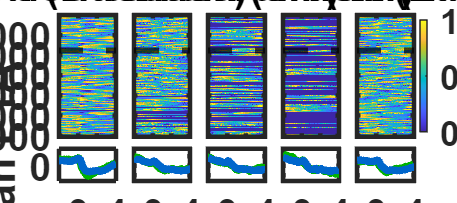

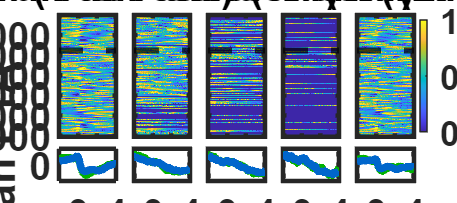

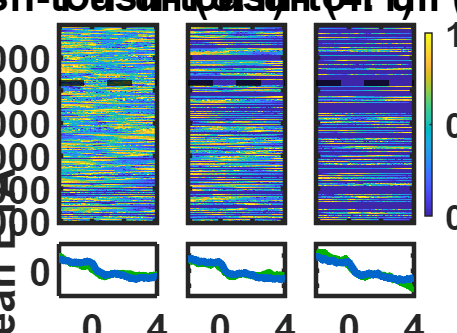

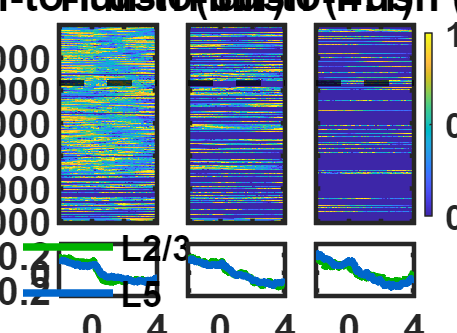

if unified2604
    fprintf('\n========== Plotting ETAs sorted by Depth (Boundary Shift) ==========\n');
    
    % =========================================================================
    % 1. 各細胞の L2/3・L5境界(線形補完)からの深さシフト量と層情報を結合
    % =========================================================================
    shift_conc = [];
    pA_conc = []; % 層情報を結合するための変数
    
    for i_animal = 1:length(Animal)
        % 層情報の結合
        pA_conc = [pA_conc; pointAreas_all_sessions{i_animal}];
        
        % 境界線のピクセル変換
        layer_bounds_pix = layer_bounds_um{i_animal} * (1280/4) / 1050; 
        layer_bounds_len = length(layer_bounds_pix);
        x_pix = linspace(1, 200, layer_bounds_len);
        
        % 画像の向き(image_reverse)に応じた座標の取得
        if image_reverse{i_animal} == 0
            neural_locations = [acc_neural_property_data_all_sessions{i_animal}(:,5), acc_neural_property_data_all_sessions{i_animal}(:,4)];
        elseif image_reverse{i_animal} == 1
            neural_locations = [800/4 - acc_neural_property_data_all_sessions{i_animal}(:,5), acc_neural_property_data_all_sessions{i_animal}(:,4)];                   
        elseif image_reverse{i_animal} == 2
            neural_locations = [800/4 - acc_neural_property_data_all_sessions{i_animal}(:,5), 1280/4 - acc_neural_property_data_all_sessions{i_animal}(:,4)];        
        elseif image_reverse{i_animal} == 3
            neural_locations = [acc_neural_property_data_all_sessions{i_animal}(:,5), 1280/4 - acc_neural_property_data_all_sessions{i_animal}(:,4)];           
        elseif image_reverse{i_animal} == 4
            neural_locations = [acc_neural_property_data_all_sessions{i_animal}(:,4), 800/4 - acc_neural_property_data_all_sessions{i_animal}(:,5)];    
            x_pix = linspace(1, 320, layer_bounds_len);
        end
        
        % 細胞の X 位置における境界線の Y 閾値を線形補完で求める
        threshold_y = interp1(x_pix, layer_bounds_pix, neural_locations(:,1), 'linear', 'extrap');
        
        % 境界からのシフト量を計算 (ピクセル)
        shift_pix = threshold_y - neural_locations(:,2);
        
        % ピクセルを物理スケール(μm)に戻す
        shift_um = shift_pix * 1050 / (1280/4);
        
        shift_conc = [shift_conc; shift_um];
    end
    
    % シフト順 (浅い順: マイナス -> プラス) にソートするためのインデックスを取得
    [sorted_shift, sort_order_depth] = sort(shift_conc);
    
    % ヒートマップ上で境界線(Shift=0)を引くためのY軸インデックスを取得
    boundary_y_idx = find(sorted_shift >= 0, 1, 'first');
    if isempty(boundary_y_idx), boundary_y_idx = 1; end

    % 層のインデックス（平均波形計算用）
    is_L23 = (pA_conc == 1);
    is_L5  = (pA_conc == 0);


    % =========================================================================
    % 2. ヒートマップの描画 (Depth-Sorted)
    % =========================================================================
    % グローバルスタイル設定
    set(0, 'DefaultAxesFontSize', 16);
    set(0, 'DefaultTextFontSize', 16);
    set(0, 'DefaultAxesFontWeight', 'bold');
    set(0, 'DefaultAxesLineWidth', 1.5);
    
    if norm == 1
        climit = [0 1];
    elseif ismember(norm, [2, 3, 4, 5, 7])
        climit = [-2 2];
    elseif norm == 6
        climit = [-4 4];
    else
        climit = [0 50];
    end
    
    time_axis = -before_event:0.1:after_event;
    
    %% --- 1. Push 5パネル比較 (Depth Sorted) ---
    figure('Position', [50, 100, 1800, 800], 'Color', 'w', 'Name', 'Push ETA - Depth Sorted');
    t_title_push = {'Push (Success)', 'Push-to-Pull (8:1)', 'Push-to-Pull (4:1)', 'Push-to-Pull (2:1)', 'Push (Fail)'};
    push_data = {push_success_conc, push_p2p_8_1_conc, push_p2p_4_1_conc, push_p2p_2_1_conc, push_fail_conc};
    
    % L2/3 と L5 の平均波形をそれぞれ計算
    push_means_L23 = cellfun(@(x) mean(x(is_L23, :), 1, 'omitnan'), push_data, 'UniformOutput', false);
    push_means_L5  = cellfun(@(x) mean(x(is_L5, :), 1, 'omitnan'), push_data, 'UniformOutput', false);
    
    tmp_push = [cell2mat(push_means_L23'); cell2mat(push_means_L5')];
    ylim_line_push = [min(tmp_push(:)) - 0.1, max(tmp_push(:)) + 0.1];
    if isnan(ylim_line_push(1)) || ylim_line_push(1) >= ylim_line_push(2), ylim_line_push = [-1, 1]; end

    for i = 1:5
        % ヒートマップ
        subplot(4, 5, [i, i+5, i+10]);
        sorted_image = push_data{i}(sort_order_depth, :);
        h = imagesc(time_axis, 1:size(sorted_image, 1), sorted_image, climit);
        
        hold on;
        
        % ★ 境界線を描画 (文字なし)
        yline(boundary_y_idx, 'k--', 'LineWidth', 2);
        
        title(t_title_push{i}, 'FontSize', 18, 'FontWeight', 'bold');
        set(gca, 'XTickLabel', []);
        
        if i == 1
            ylabel('Cell (Sorted by Depth)', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on; axis tight;
        
        % 平均波形 (L2/3: 緑, L5: 青)
        subplot(4, 5, i+15); hold on;
        plot(time_axis, push_means_L23{i}, 'Color', [0 0.7 0], 'LineWidth', 2.5); % L2/3 (Green)
        plot(time_axis, push_means_L5{i},  'Color', [0 0.4 0.8], 'LineWidth', 2.5); % L5 (Blue)
        
        xlim([time_axis(1) time_axis(end)]);
        ylim(ylim_line_push);
        xlabel('Time (sec)', 'FontSize', 16);
        
        if i == 1
            ylabel('Mean ETA', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on;
    end
    
    cb1 = colorbar;
    cb1.Position = [0.92 0.35 0.015 0.55]; 
    cb1.Label.String = 'Activity (Z-score)';
    cb1.Label.FontSize = 16;
    saveas(gcf, fullfile(output_dir, 'Push_5panels_heatmap_DepthSorted.png'));
    
    
    %% --- 2. Pull 5パネル比較 (Depth Sorted) ---
    figure('Position', [50, 300, 1800, 800], 'Color', 'w', 'Name', 'Pull ETA - Depth Sorted');
    t_title_pull = {'Pull (Success)', 'Pull-to-Push (8:1)', 'Pull-to-Push (4:1)', 'Pull-to-Push (2:1)', 'Pull (Fail)'};
    pull_data = {pull_success_conc, pull_p2push_8_1_conc, pull_p2push_4_1_conc, pull_p2push_2_1_conc, pull_fail_conc};
    
    pull_means_L23 = cellfun(@(x) mean(x(is_L23, :), 1, 'omitnan'), pull_data, 'UniformOutput', false);
    pull_means_L5  = cellfun(@(x) mean(x(is_L5, :), 1, 'omitnan'), pull_data, 'UniformOutput', false);
    
    tmp_pull = [cell2mat(pull_means_L23'); cell2mat(pull_means_L5')];
    ylim_line_pull = [min(tmp_pull(:)) - 0.1, max(tmp_pull(:)) + 0.1];
    if isnan(ylim_line_pull(1)) || ylim_line_pull(1) >= ylim_line_pull(2), ylim_line_pull = [-1, 1]; end

    for i = 1:5
        subplot(4, 5, [i, i+5, i+10]);
        sorted_image = pull_data{i}(sort_order_depth, :);
        h = imagesc(time_axis, 1:size(sorted_image, 1), sorted_image, climit);

        hold on;
        
        yline(boundary_y_idx, 'k--', 'LineWidth', 2);
        
        title(t_title_pull{i}, 'FontSize', 18, 'FontWeight', 'bold');
        set(gca, 'XTickLabel', []);
        
        if i == 1
            ylabel('Cell (Sorted by Depth)', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on; axis tight;
        
        subplot(4, 5, i+15); hold on;
        plot(time_axis, pull_means_L23{i}, 'Color', [0 0.7 0], 'LineWidth', 2.5);
        plot(time_axis, pull_means_L5{i},  'Color', [0 0.4 0.8], 'LineWidth', 2.5);
        
        set(gca, 'Color', 'w');
        xlim([time_axis(1) time_axis(end)]);
        ylim(ylim_line_pull);
        xlabel('Time (sec)', 'FontSize', 16);
        
        if i == 1
            ylabel('Mean ETA', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on;
    end
    
    cb2 = colorbar;
    cb2.Position = [0.92 0.35 0.015 0.55]; 
    cb2.Label.String = 'Activity (Z-score)';
    cb2.Label.FontSize = 16;
    saveas(gcf, fullfile(output_dir, 'Pull_5panels_heatmap_DepthSorted.png'));


    %% --- 3. Push-to-Pull (最後のPull基準) 3パネル (Depth Sorted) ---
    figure('Position', [100, 100, 1100, 800], 'Color', 'w', 'Name', 'Push-to-Pull ETA - Depth Sorted');
    t_title_p2p = {'Push-to-Pull (8:1)', 'Push-to-Pull (4:1)', 'Push-to-Pull (2:1)'};
    data_p2p = {p2p_pull_8_1_conc, p2p_pull_4_1_conc, p2p_pull_2_1_conc};
    
    p2p_means_L23 = cellfun(@(x) mean(x(is_L23, :), 1, 'omitnan'), data_p2p, 'UniformOutput', false);
    p2p_means_L5  = cellfun(@(x) mean(x(is_L5, :), 1, 'omitnan'), data_p2p, 'UniformOutput', false);
    
    tmp_p2p = [cell2mat(p2p_means_L23'); cell2mat(p2p_means_L5')];
    ylim_line_p2p = [min(tmp_p2p(:)) - 0.1, max(tmp_p2p(:)) + 0.1];
    if isnan(ylim_line_p2p(1)) || ylim_line_p2p(1) >= ylim_line_p2p(2), ylim_line_p2p = [-1, 1]; end

    for i = 1:3
        subplot(4, 3, [i, i+3, i+6]);
        sorted_image = data_p2p{i}(sort_order_depth, :);
        h = imagesc(time_axis, 1:size(sorted_image, 1), sorted_image, climit);

        hold on;
        
        yline(boundary_y_idx, 'k--', 'LineWidth', 2);
        
        title(t_title_p2p{i}, 'FontSize', 18, 'FontWeight', 'bold');
        set(gca, 'XTickLabel', []);
        
        if i == 1
            ylabel('Cell (Sorted by Depth)', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on; axis tight;
        
        subplot(4, 3, i+9); hold on;
        plot(time_axis, p2p_means_L23{i}, 'Color', [0 0.7 0], 'LineWidth', 2.5);
        plot(time_axis, p2p_means_L5{i},  'Color', [0 0.4 0.8], 'LineWidth', 2.5);
        
        set(gca, 'Color', 'w');
        xlim([time_axis(1) time_axis(end)]);
        ylim(ylim_line_p2p);
        xlabel('Time (sec)', 'FontSize', 16);
        
        if i == 1
            ylabel('Mean ETA', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on;
    end
    
    cb3 = colorbar;
    cb3.Position = [0.93 0.35 0.015 0.55]; 
    cb3.Label.String = 'Activity (Z-score)';
    saveas(gcf, fullfile(output_dir, 'Push_to_Pull_LastPull_3panels_DepthSorted.png'));
    
    
    %% --- 4. Pull-to-Push (最後のPush基準) 3パネル (Depth Sorted) ---
    figure('Position', [100, 300, 1100, 800], 'Color', 'w', 'Name', 'Pull-to-Push ETA - Depth Sorted');
    t_title_p2push = {'Pull-to-Push (8:1)', 'Pull-to-Push (4:1)', 'Pull-to-Push (2:1)'};
    data_p2push = {p2push_push_8_1_conc, p2push_push_4_1_conc, p2push_push_2_1_conc};
    
    p2push_means_L23 = cellfun(@(x) mean(x(is_L23, :), 1, 'omitnan'), data_p2push, 'UniformOutput', false);
    p2push_means_L5  = cellfun(@(x) mean(x(is_L5, :), 1, 'omitnan'), data_p2push, 'UniformOutput', false);
    
    tmp_p2push = [cell2mat(p2push_means_L23'); cell2mat(p2push_means_L5')];
    ylim_line_p2push = [min(tmp_p2push(:)) - 0.1, max(tmp_p2push(:)) + 0.1];
    if isnan(ylim_line_p2push(1)) || ylim_line_p2push(1) >= ylim_line_p2push(2), ylim_line_p2push = [-1, 1]; end

    for i = 1:3
        subplot(4, 3, [i, i+3, i+6]);
        sorted_image = data_p2push{i}(sort_order_depth, :);
        h = imagesc(time_axis, 1:size(sorted_image, 1), sorted_image, climit);

        hold on;
        
        yline(boundary_y_idx, 'k--', 'LineWidth', 2);
        
        title(t_title_p2push{i}, 'FontSize', 18, 'FontWeight', 'bold');
        set(gca, 'XTickLabel', []);
        
        if i == 1
            ylabel('Cell (Sorted by Depth)', 'FontSize', 16);
        else
            set(gca, 'YTickLabel', []);
        end
        box on; axis tight;
        
        subplot(4, 3, i+9); hold on;
        plot(time_axis, p2push_means_L23{i}, 'Color', [0 0.7 0], 'LineWidth', 2.5);
        plot(time_axis, p2push_means_L5{i},  'Color', [0 0.4 0.8], 'LineWidth', 2.5);
        
        set(gca, 'Color', 'w');
        xlim([time_axis(1) time_axis(end)]);
        ylim(ylim_line_p2push);
        xlabel('Time (sec)', 'FontSize', 16);
        
        if i == 1
            ylabel('Mean ETA', 'FontSize', 16);
            legend('L2/3', 'L5', 'Location', 'best', 'FontSize', 12, 'Box', 'off'); % 凡例を追加
        else
            set(gca, 'YTickLabel', []);
        end
        box on;
    end
    
    cb4 = colorbar;
    cb4.Position = [0.93 0.35 0.015 0.55]; 
    cb4.Label.String = 'Activity (Z-score)';
    saveas(gcf, fullfile(output_dir, 'Pull_to_Push_LastPush_3panels_DepthSorted.png'));
end

% % climit = [0 50];
% figure
% set(gcf,'color','w');
% 
% clims = climit;  % カラーマップのスケーリング
% image = force_act_conc;
% 
% % グレースケールのカラーマップ
% colormap(gray);
% 
% % ヒートマップ描画
% imagesc(-before_event:0.1:after_event, 1:size(force_act_conc,1), image, clims);
% 
% % 軸ラベル
% ylabel('cell');
% xlabel('time (sec)');
% 
% % 0秒位置に縦線
% hold on;
% xline(0, 'k--', 'LineWidth', 2.0);  % 黒の破線
% 
% % アスペクト比を正方形に近づける
% % axis tight;
% % axis equal;
% pbaspect([1 1 1]);  % 幅:高さ:奥行き = 1:1:1 に調整
% 
% % カラーバー（必要であれば）
% % colorbar;
% 
% % 保存
% filename = [output_dir 'force_eta_activity_heatmap_DC.png'];
% saveas(gcf, filename);
% close(gcf);


% =========================================================================
% Cross-session Granger Causality Analysis Block
% PC-number sensitivity analysis
% =========================================================================
% Run only if GC is 1 and categorize is 'layer'
if exist('GC', 'var') && GC == 1 && strcmp(categorize, 'layer') == 1
    
    fprintf('\n======================================================\n');
    fprintf('Starting cross-session Granger Causality analysis...\n');
    fprintf('PC-number sensitivity analysis\n');
    fprintf('======================================================\n');

    addpath(genpath("C:\Users\Naohiro\Documents\MATLAB\Makino2022\Utility\custom"));
    addpath(genpath("C:\Users\Naohiro\Documents\MATLAB\Makino2022\Utility\github_repo"));
    p = gcp('nocreate');

    % プールがない、またはワーカー数が最適でない場合は再構築
    desired_workers = 10; % 物理コア数である10をベースに設定 (最大16程度まで増量可能)
    if isempty(p) || p.NumWorkers ~= desired_workers
        delete(gcp('nocreate')); % 既存のプールを閉じる
        parpool('local', desired_workers); % 10ワーカーでプールを起動
    end

    % ---------------------------------------------------------------------
    % Settings
    % ---------------------------------------------------------------------
    cond_names   = {'Pull', 'Push', 'Force'};  % Force = Pull + Push
    num_pcs_list = [3 5 10 15];                % PC sensitivity analysis
    alpha_gc     = 0.01;                       % Significance level
    max_lag      = 20;                         % AIC search range: 1–20
    regmode      = 'OLS';
    
    time_len  = fps * (before_event + after_event) + 1;
    onset_idx = fps * before_event + 1;

    % ---------------------------------------------------------------------
    % Logging control
    % ---------------------------------------------------------------------
    verbose_skip = false;      % true のとき skip理由を表示
    progress_step = 20;        % 20ジョブごとに進捗表示
    job_counter = 0;
    total_jobs = length(num_pcs_list) * length(cond_names);
    
    % ---------------------------------------------------------------------
    % Initialize result structure
    % stats_GC.PC3.Pull, stats_GC.PC5.Pull, ...
    % ---------------------------------------------------------------------
    stats_GC = struct();
    
    for p_i = 1:length(num_pcs_list)
        num_pcs = num_pcs_list(p_i);
        pc_field = sprintf('PC%d', num_pcs);
        
        for c = 1:length(cond_names)
            cond = cond_names{c};
            
            stats_GC.(pc_field).(cond).Animal_Date = {};
            
            % Unweighted GC summaries
            stats_GC.(pc_field).(cond).A_23_to_5 = [];
            stats_GC.(pc_field).(cond).A_5_to_23 = [];
            stats_GC.(pc_field).(cond).B_23_to_5 = [];
            stats_GC.(pc_field).(cond).B_5_to_23 = [];
            stats_GC.(pc_field).(cond).DI        = [];
            
            % Explained-variance-weighted GC summaries
            stats_GC.(pc_field).(cond).W_23_to_5 = [];
            stats_GC.(pc_field).(cond).W_5_to_23 = [];
            stats_GC.(pc_field).(cond).WDI       = [];
            
            % PCA explained variance
            stats_GC.(pc_field).(cond).Explained_23 = [];
            stats_GC.(pc_field).(cond).Explained_5  = [];
            
            % Diagnostics
            stats_GC.(pc_field).(cond).Model_Order = [];
            stats_GC.(pc_field).(cond).Num_Trials  = [];
        end
    end
    
    % ---------------------------------------------------------------------
    % Main loop: PC number x session x condition
    % ---------------------------------------------------------------------
    for p_i = 1:length(num_pcs_list)
        num_pcs = num_pcs_list(p_i);
        pc_field = sprintf('PC%d', num_pcs);
    
        for c = 1:length(cond_names)
            cond = cond_names{c};
    
            % parfor output container
            results_session = cell(1, length(Animal));
    
            parfor i_animal = 1:length(Animal)
    
                % -------------------------------------------------------------
                % Each worker computes GC for one session
                % -------------------------------------------------------------
                result = struct();
                result.success = false;
    
                try
                    curr_raw_data   = acc_neural_activity_data_all_sessions{i_animal};
                    curr_pointAreas = pointAreas_all_sessions{i_animal};
    
                    layer23_cell_indices = find(curr_pointAreas == 1);
                    layer5_cell_indices  = find(curr_pointAreas == 0);
    
                    if length(layer23_cell_indices) < num_pcs || length(layer5_cell_indices) < num_pcs
                        result.message = 'Insufficient cells';
                        results_session{i_animal} = result;
                        continue;
                    end
    
                    pull_idxs = force_idx_sessions{i_animal};
                    push_idxs = force_idx2_sessions{i_animal};
                    force_all_idxs = sort([pull_idxs(:); push_idxs(:)]);
    
                    switch cond
                        case 'Pull'
                            curr_event_idxs = pull_idxs;
                        case 'Push'
                            curr_event_idxs = push_idxs;
                        case 'Force'
                            curr_event_idxs = force_all_idxs;
                    end
    
                    valid_acts = {};
    
                    for j = 1:length(curr_event_idxs)
                        idx = curr_event_idxs(j);
                        start_idx = round(idx - fps * before_event);
                        end_idx   = round(idx + fps * after_event);
    
                        if start_idx > 0 && end_idx <= size(curr_raw_data, 1)
                            valid_acts{end+1} = curr_raw_data(start_idx:end_idx, :)';
                        end
                    end
    
                    num_trials = length(valid_acts);
    
                    if num_trials < 2
                        result.message = 'Insufficient valid trials';
                        results_session{i_animal} = result;
                        continue;
                    end
    
                    time_len_local  = fps * (before_event + after_event) + 1;
                    onset_idx_local = fps * before_event + 1;
    
                    acts_3d = reshape(cell2mat(valid_acts), ...
                        [size(curr_raw_data, 2), time_len_local, num_trials]);
    
                    data_layer23_raw = acts_3d(layer23_cell_indices, :, :);
                    data_layer5_raw  = acts_3d(layer5_cell_indices, :, :);
    
                    flat_layer23 = reshape(data_layer23_raw, length(layer23_cell_indices), []);
                    flat_layer5  = reshape(data_layer5_raw,  length(layer5_cell_indices),  []);
    
                    [~, score23, ~, ~, explained23] = pca(flat_layer23');
                    [~, score5,  ~, ~, explained5]  = pca(flat_layer5');
    
                    if size(score23, 2) < num_pcs || size(score5, 2) < num_pcs
                        result.message = 'Insufficient PCA components';
                        results_session{i_animal} = result;
                        continue;
                    end
    
                    reduced_layer23 = reshape(score23(:, 1:num_pcs)', num_pcs, time_len_local, num_trials);
                    reduced_layer5  = reshape(score5(:,  1:num_pcs)', num_pcs, time_len_local, num_trials);
    
                    data_pcs = [reduced_layer23; reduced_layer5];
                    num_total_variables = size(data_pcs, 1);
    
                    % Baseline subtraction
                    for trial = 1:num_trials
                        for v = 1:num_total_variables
                            onset_value = data_pcs(v, onset_idx_local, trial);
                            data_pcs(v, :, trial) = data_pcs(v, :, trial) - onset_value;
                        end
                    end
    
                    data_concat = reshape(data_pcs, num_total_variables, []);
    
                    if any(isnan(data_concat(:))) || any(isinf(data_concat(:)))
                        result.message = 'NaN or Inf in data';
                        results_session{i_animal} = result;
                        continue;
                    end
    
                    pc_std = std(data_concat, 0, 2);
                    if any(pc_std < 1e-10)
                        result.message = 'Near-zero PC variance';
                        results_session{i_animal} = result;
                        continue;
                    end
    
                    try
                        model_order = estimate_model_order(data_concat, max_lag, regmode);
                    catch
                        model_order = 2;
                    end
    
                    if isempty(model_order) || isnan(model_order) || model_order < 1
                        model_order = 2;
                    end
    
                    model_order = min(model_order, max_lag);
    
                    df2 = size(data_concat, 2) - model_order * num_total_variables - 1;
    
                    if df2 <= 0
                        result.message = 'df2 <= 0';
                        results_session{i_animal} = result;
                        continue;
                    end
    
                    F = mvgc_analysis(data_concat, model_order, alpha_gc, regmode);
    
                    if isempty(F) || any(isnan(F(:))) || any(isinf(F(:)))
                        result.message = 'Bad GC matrix';
                        results_session{i_animal} = result;
                        continue;
                    end
    
                    df1 = model_order;
                    pval = 1 - fcdf(F, df1, df2);
    
                    idx_23 = 1:num_pcs;
                    idx_5  = (num_pcs+1):num_total_variables;
    
                    F_23_to_5 = F(idx_5,  idx_23);
                    F_5_to_23 = F(idx_23, idx_5);
    
                    p_23_to_5 = pval(idx_5,  idx_23);
                    p_5_to_23 = pval(idx_23, idx_5);
    
                    A_23_to_5 = sum(F_23_to_5(:));
                    A_5_to_23 = sum(F_5_to_23(:));
    
                    B_23_to_5 = sum(p_23_to_5(:) < alpha_gc);
                    B_5_to_23 = sum(p_5_to_23(:) < alpha_gc);
    
                    DI = (A_23_to_5 - A_5_to_23) / ...
                         (A_23_to_5 + A_5_to_23 + 1e-10);
    
                    % Explained-variance weights
                    w23 = explained23(1:num_pcs);
                    w5  = explained5(1:num_pcs);
    
                    w23 = w23(:) / sum(w23);
                    w5  = w5(:)  / sum(w5);
    
                    W_23_to_5 = sum(sum(F_23_to_5 .* (w5 * w23')));
                    W_5_to_23 = sum(sum(F_5_to_23 .* (w23 * w5')));
    
                    WDI = (W_23_to_5 - W_5_to_23) / ...
                          (W_23_to_5 + W_5_to_23 + 1e-10);
    
                    % Save result for this session
                    result.success = true;
                    result.Animal_Date = sprintf('%s_%s', ...
                        strjoin(Animal(i_animal)), strjoin(Date(i_animal)));
    
                    result.A_23_to_5 = A_23_to_5;
                    result.A_5_to_23 = A_5_to_23;
                    result.B_23_to_5 = B_23_to_5;
                    result.B_5_to_23 = B_5_to_23;
                    result.DI        = DI;
    
                    result.W_23_to_5 = W_23_to_5;
                    result.W_5_to_23 = W_5_to_23;
                    result.WDI       = WDI;
    
                    result.Explained_23 = sum(explained23(1:num_pcs));
                    result.Explained_5  = sum(explained5(1:num_pcs));
    
                    result.Model_Order = model_order;
                    result.Num_Trials  = num_trials;
                    result.message = 'OK';
    
                    results_session{i_animal} = result;
    
                catch ME
                    result.success = false;
                    result.message = ME.message;
                    result.identifier = ME.identifier;
                    results_session{i_animal} = result;
                end
            end
    
            % -----------------------------------------------------------------
            % Merge parfor results into stats_GC outside parfor
            % -----------------------------------------------------------------
            for i_animal = 1:length(Animal)
                result = results_session{i_animal};
    
                if isempty(result) || ~isfield(result, 'success') || ~result.success
                    if verbose_skip && ~isempty(result) && isfield(result, 'message')
                        fprintf('[DEBUG] PC%d, %s, Session %d skipped: %s\n', ...
                            num_pcs, cond, i_animal, result.message);
                    end
                    continue;
                end
    
                stats_GC.(pc_field).(cond).Animal_Date{end+1} = result.Animal_Date;
    
                stats_GC.(pc_field).(cond).A_23_to_5(end+1) = result.A_23_to_5;
                stats_GC.(pc_field).(cond).A_5_to_23(end+1) = result.A_5_to_23;
                stats_GC.(pc_field).(cond).B_23_to_5(end+1) = result.B_23_to_5;
                stats_GC.(pc_field).(cond).B_5_to_23(end+1) = result.B_5_to_23;
                stats_GC.(pc_field).(cond).DI(end+1)        = result.DI;
    
                stats_GC.(pc_field).(cond).W_23_to_5(end+1) = result.W_23_to_5;
                stats_GC.(pc_field).(cond).W_5_to_23(end+1) = result.W_5_to_23;
                stats_GC.(pc_field).(cond).WDI(end+1)       = result.WDI;
    
                stats_GC.(pc_field).(cond).Explained_23(end+1) = result.Explained_23;
                stats_GC.(pc_field).(cond).Explained_5(end+1)  = result.Explained_5;
    
                stats_GC.(pc_field).(cond).Model_Order(end+1) = result.Model_Order;
                stats_GC.(pc_field).(cond).Num_Trials(end+1)  = result.Num_Trials;
            end
        end
    end
    
    % ---------------------------------------------------------------------
    % Save statistics summary
    % ---------------------------------------------------------------------
    txt_filename = fullfile(output_dir, sprintf('%s_GC_PC_Sensitivity_Summary.txt', strjoin(Date(1))));
    fid = fopen(txt_filename, 'w');
    
    msg = '\n===== Cross-session GC PC Sensitivity Statistics =====\n';
    fprintf(msg); fprintf(fid, msg);
    
    for p_i = 1:length(num_pcs_list)
        num_pcs = num_pcs_list(p_i);
        pc_field = sprintf('PC%d', num_pcs);
        
        msg = sprintf('\n======================================================\nPC number: %d\n======================================================\n', num_pcs);
        fprintf(msg); fprintf(fid, msg);
        
        for c = 1:length(cond_names)
            cond = cond_names{c};
            N_sess = length(stats_GC.(pc_field).(cond).A_23_to_5);
            
            msg = sprintf('\n--- %s Condition, %s (N = %d sessions) ---\n', cond, pc_field, N_sess);
            fprintf(msg); fprintf(fid, msg);
            
            if N_sess < 3
                msg = 'Not enough sessions for statistics.\n';
                fprintf(msg); fprintf(fid, msg);
                continue;
            end
            
            val_A_23to5 = stats_GC.(pc_field).(cond).A_23_to_5;
            val_A_5to23 = stats_GC.(pc_field).(cond).A_5_to_23;
            p_A = signrank(val_A_23to5, val_A_5to23);
            
            msg = sprintf(['Indicator A: Total Causal Flow, unweighted\n', ...
                '  L2/3->L5 Median: %.4f\n', ...
                '  L5->L2/3 Median: %.4f\n', ...
                '  Wilcoxon p: %.4e\n'], ...
                median(val_A_23to5), median(val_A_5to23), p_A);
            fprintf(msg); fprintf(fid, msg);
            
            val_B_23to5 = stats_GC.(pc_field).(cond).B_23_to_5;
            val_B_5to23 = stats_GC.(pc_field).(cond).B_5_to_23;
            p_B = signrank(val_B_23to5, val_B_5to23);
            
            msg = sprintf(['Indicator B: Significant Edges\n', ...
                '  L2/3->L5 Median: %.1f\n', ...
                '  L5->L2/3 Median: %.1f\n', ...
                '  Wilcoxon p: %.4e\n'], ...
                median(val_B_23to5), median(val_B_5to23), p_B);
            fprintf(msg); fprintf(fid, msg);
            
            val_DI = stats_GC.(pc_field).(cond).DI;
            p_DI = signrank(val_DI);
            
            msg = sprintf(['Indicator C: Directionality Index, unweighted\n', ...
                '  DI Median: %.4f\n', ...
                '  DI vs 0 p: %.4e\n'], ...
                median(val_DI), p_DI);
            fprintf(msg); fprintf(fid, msg);
            
            val_W_23to5 = stats_GC.(pc_field).(cond).W_23_to_5;
            val_W_5to23 = stats_GC.(pc_field).(cond).W_5_to_23;
            p_W = signrank(val_W_23to5, val_W_5to23);
            
            msg = sprintf(['Indicator D: Explained-variance-weighted GC\n', ...
                '  Weighted L2/3->L5 Median: %.4f\n', ...
                '  Weighted L5->L2/3 Median: %.4f\n', ...
                '  Wilcoxon p: %.4e\n'], ...
                median(val_W_23to5), median(val_W_5to23), p_W);
            fprintf(msg); fprintf(fid, msg);
            
            val_WDI = stats_GC.(pc_field).(cond).WDI;
            p_WDI = signrank(val_WDI);
            
            msg = sprintf(['Indicator E: Weighted Directionality Index\n', ...
                '  WDI Median: %.4f\n', ...
                '  WDI vs 0 p: %.4e\n'], ...
                median(val_WDI), p_WDI);
            fprintf(msg); fprintf(fid, msg);
            
            msg = sprintf(['PCA variance retained\n', ...
                '  L2/3 Median explained variance: %.2f%%\n', ...
                '  L5 Median explained variance: %.2f%%\n'], ...
                median(stats_GC.(pc_field).(cond).Explained_23), ...
                median(stats_GC.(pc_field).(cond).Explained_5));
            fprintf(msg); fprintf(fid, msg);
        end
    end
    
    msg = '\n======================================================\n';
    fprintf(msg); fprintf(fid, msg);
    fclose(fid);
    
    % Save full result structure
    mat_filename = fullfile(output_dir, sprintf('%s_GC_PC_Sensitivity_Stats.mat', strjoin(Date(1))));
    save(mat_filename, 'stats_GC', 'num_pcs_list', 'cond_names', 'alpha_gc', 'max_lag');
    
    % % ---------------------------------------------------------------------
    % % Visualization: sensitivity of DI and weighted DI across PC numbers
    % % ---------------------------------------------------------------------
    % set(0, 'DefaultAxesFontName', 'Arial');
    % set(0, 'DefaultTextFontName', 'Arial');
    % set(0, 'DefaultAxesFontSize', 7);
    % 
    % for c = 1:length(cond_names)
    %     cond = cond_names{c};
    % 
    %     med_DI  = nan(1, length(num_pcs_list));
    %     med_WDI = nan(1, length(num_pcs_list));
    %     n_sess  = nan(1, length(num_pcs_list));
    % 
    %     for p_i = 1:length(num_pcs_list)
    %         pc_field = sprintf('PC%d', num_pcs_list(p_i));
    % 
    %         data_DI  = stats_GC.(pc_field).(cond).DI;
    %         data_WDI = stats_GC.(pc_field).(cond).WDI;
    % 
    %         if ~isempty(data_DI)
    %             med_DI(p_i) = median(data_DI);
    %             n_sess(p_i) = length(data_DI);
    %         end
    % 
    %         if ~isempty(data_WDI)
    %             med_WDI(p_i) = median(data_WDI);
    %         end
    %     end
    % 
    %     fig = figure('Units', 'centimeters', 'Position', [2, 2, 10, 6], 'Color', 'w');
    %     hold on;
    % 
    %     plot(num_pcs_list, med_DI, '-o', 'LineWidth', 1.2, 'MarkerSize', 4);
    %     plot(num_pcs_list, med_WDI, '-s', 'LineWidth', 1.2, 'MarkerSize', 4);
    %     yline(0, '--k', 'LineWidth', 0.5);
    % 
    %     xlabel('Number of PCs per layer');
    %     ylabel('Directionality index');
    %     title(sprintf('GC Directionality Sensitivity: %s', cond));
    %     legend({'Unweighted DI', 'Variance-weighted DI'}, 'Location', 'best', 'Box', 'off');
    %     set(gca, 'LineWidth', 0.5, 'Box', 'off');
    % 
    %     % Add N labels
    %     y_lim = ylim;
    %     for p_i = 1:length(num_pcs_list)
    %         if ~isnan(n_sess(p_i))
    %             text(num_pcs_list(p_i), y_lim(1) + 0.05 * range(y_lim), ...
    %                 sprintf('N=%d', n_sess(p_i)), ...
    %                 'HorizontalAlignment', 'center', ...
    %                 'FontSize', 6);
    %         end
    %     end
    % 
    %     pdf_filename = fullfile(output_dir, sprintf('%s_GC_PC_Sensitivity_DI_%s.pdf', ...
    %         strjoin(Date(1)), cond));
    %     exportgraphics(fig, pdf_filename, 'ContentType', 'vector');
    %     close(fig);
    % end
    % 
    % fprintf('\nGC PC sensitivity analysis completed.\n');
    % fprintf('Summary saved to: %s\n', txt_filename);
    % fprintf('MAT file saved to: %s\n', mat_filename);
end

if exist('GC', 'var') && GC == 1 && strcmp(categorize, 'layer') == 1
    % ---------------------------------------------------------------------
    % Visualization:
    % 1) Directionality index sensitivity (DI / WDI) with mean ± SEM
    % 2) Total causal flow sensitivity (L2/3->L5 vs L5->L2/3) with mean ± SEM
    %    and significance markers
    % ---------------------------------------------------------------------
    set(0, 'DefaultAxesFontName', 'Arial');
    set(0, 'DefaultTextFontName', 'Arial');
    set(0, 'DefaultAxesFontSize', 7);
    
    color_green = [0.4660, 0.6740, 0.1880]; % L2/3 -> L5
    color_blue  = [0.0000, 0.4470, 0.7410]; % L5 -> L2/3
    color_gray1 = [0.35 0.35 0.35];         % DI
    color_gray2 = [0.60 0.60 0.60];         % WDI
    
    get_star = @(p) repmat('*', 1, (p<0.05) + (p<0.01) + (p<0.001));
    
    for c = 1:length(cond_names)
        cond = cond_names{c};
        
        % -------------------------------------------------------------
        % Collect summary values across PC numbers
        % -------------------------------------------------------------
        mean_DI   = nan(1, length(num_pcs_list));
        sem_DI    = nan(1, length(num_pcs_list));
        mean_WDI  = nan(1, length(num_pcs_list));
        sem_WDI   = nan(1, length(num_pcs_list));
        n_sess    = nan(1, length(num_pcs_list));
        p_DI0     = nan(1, length(num_pcs_list));   % DI vs 0
        p_WDI0    = nan(1, length(num_pcs_list));   % WDI vs 0
        
        mean_A23  = nan(1, length(num_pcs_list));
        sem_A23   = nan(1, length(num_pcs_list));
        mean_A5   = nan(1, length(num_pcs_list));
        sem_A5    = nan(1, length(num_pcs_list));
        p_Apair   = nan(1, length(num_pcs_list));   % L2/3->L5 vs L5->L2/3
        
        for p_i = 1:length(num_pcs_list)
            pc_field = sprintf('PC%d', num_pcs_list(p_i));
            
            data_DI   = stats_GC.(pc_field).(cond).DI;
            data_WDI  = stats_GC.(pc_field).(cond).WDI;
            data_A23  = stats_GC.(pc_field).(cond).A_23_to_5;
            data_A5   = stats_GC.(pc_field).(cond).A_5_to_23;
            
            if ~isempty(data_DI)
                mean_DI(p_i) = mean(data_DI, 'omitnan');
                sem_DI(p_i)  = std(data_DI, 0, 'omitnan') / sqrt(length(data_DI));
                n_sess(p_i)  = length(data_DI);
                if length(data_DI) >= 3
                    p_DI0(p_i) = signrank(data_DI);
                end
            end
            
            if ~isempty(data_WDI)
                mean_WDI(p_i) = mean(data_WDI, 'omitnan');
                sem_WDI(p_i)  = std(data_WDI, 0, 'omitnan') / sqrt(length(data_WDI));
                if length(data_WDI) >= 3
                    p_WDI0(p_i) = signrank(data_WDI);
                end
            end
            
            if ~isempty(data_A23)
                mean_A23(p_i) = mean(data_A23, 'omitnan');
                sem_A23(p_i)  = std(data_A23, 0, 'omitnan') / sqrt(length(data_A23));
            end
            
            if ~isempty(data_A5)
                mean_A5(p_i)  = mean(data_A5, 'omitnan');
                sem_A5(p_i)   = std(data_A5, 0, 'omitnan') / sqrt(length(data_A5));
            end
            
            if ~isempty(data_A23) && ~isempty(data_A5) && length(data_A23) >= 3 && length(data_A5) >= 3
                p_Apair(p_i) = signrank(data_A23, data_A5);
            end
        end
        
        % =============================================================
        % Figure 1: DI / WDI sensitivity with mean ± SEM
        % =============================================================
        fig1 = figure('Units', 'centimeters', 'Position', [2, 2, 10, 6], 'Color', 'w');
        hold on;
        
        errorbar(num_pcs_list, mean_DI,  sem_DI,  '-o', ...
            'LineWidth', 1.2, 'MarkerSize', 4, ...
            'Color', color_gray1, 'MarkerFaceColor', color_gray1);
        
        errorbar(num_pcs_list, mean_WDI, sem_WDI, '-s', ...
            'LineWidth', 1.2, 'MarkerSize', 4, ...
            'Color', color_gray2, 'MarkerFaceColor', color_gray2);
        
        yline(0, '--k', 'LineWidth', 0.5);
        
        xlabel('Number of PCs per layer');
        ylabel('Directionality index');
        title(sprintf('GC Directionality Sensitivity: %s', cond));
        legend({'Unweighted DI', 'Variance-weighted DI'}, 'Location', 'best', 'Box', 'off');
        set(gca, 'LineWidth', 0.5, 'Box', 'off');
        
        % Add N labels
        y_lim = ylim;
        for p_i = 1:length(num_pcs_list)
            if ~isnan(n_sess(p_i))
                text(num_pcs_list(p_i), y_lim(1) + 0.05 * range(y_lim), ...
                    sprintf('N=%d', n_sess(p_i)), ...
                    'HorizontalAlignment', 'center', ...
                    'FontSize', 6);
            end
        end
        
        % Add DI-vs-0 significance marker above each point
        y_lim = ylim;
        for p_i = 1:length(num_pcs_list)
            if ~isnan(p_DI0(p_i))
                sig_str = get_star(p_DI0(p_i));
                if isempty(sig_str), sig_str = 'n.s.'; end
                text(num_pcs_list(p_i), mean_DI(p_i) + sem_DI(p_i) + 0.06 * range(y_lim), ...
                    sig_str, 'HorizontalAlignment', 'center', 'FontSize', 6, 'Color', color_gray1);
            end
        end
        
        pdf_filename1 = fullfile(output_dir, sprintf('%s_GC_PC_Sensitivity_DI_%s.pdf', ...
            strjoin(Date(1)), cond));
        exportgraphics(fig1, pdf_filename1, 'ContentType', 'vector');
        close(fig1);
        
        % =============================================================
        % Figure 2: Total Causal Flow sensitivity with mean ± SEM
        % =============================================================
        fig2 = figure('Units', 'centimeters', 'Position', [2, 2, 11, 6], 'Color', 'w');
        hold on;
        
        x1 = num_pcs_list - 0.18;
        x2 = num_pcs_list + 0.18;
        
        errorbar(x1, mean_A23, sem_A23, '-o', ...
            'LineWidth', 1.2, 'MarkerSize', 4, ...
            'Color', color_green, 'MarkerFaceColor', color_green);
        
        errorbar(x2, mean_A5, sem_A5, '-o', ...
            'LineWidth', 1.2, 'MarkerSize', 4, ...
            'Color', color_blue, 'MarkerFaceColor', color_blue);
        
        xlabel('Number of PCs per layer');
        ylabel('Total Causal Flow (Sum of F)');
        title(sprintf('GC Total Causal Flow Sensitivity: %s', cond));
        legend({'L2/3 \rightarrow L5', 'L5 \rightarrow L2/3'}, 'Location', 'best', 'Box', 'off');
        set(gca, 'LineWidth', 0.5, 'Box', 'off');
        
        % Add N labels near bottom
        y_lim = ylim;
        for p_i = 1:length(num_pcs_list)
            if ~isnan(n_sess(p_i))
                text(num_pcs_list(p_i), y_lim(1) + 0.05 * range(y_lim), ...
                    sprintf('N=%d', n_sess(p_i)), ...
                    'HorizontalAlignment', 'center', ...
                    'FontSize', 6);
            end
        end
        
        % Add significance markers for L2/3->L5 vs L5->L2/3 at each PC number
        y_lim = ylim;
        for p_i = 1:length(num_pcs_list)
            if ~isnan(p_Apair(p_i)) && ~isnan(mean_A23(p_i)) && ~isnan(mean_A5(p_i))
                sig_str = get_star(p_Apair(p_i));
                if isempty(sig_str), sig_str = 'n.s.'; end
                
                curr_max = max([mean_A23(p_i) + sem_A23(p_i), mean_A5(p_i) + sem_A5(p_i)]);
                bar_y = curr_max + 0.06 * range(y_lim);
                text_y = curr_max + 0.10 * range(y_lim);
                
                plot([x1(p_i) x1(p_i) x2(p_i) x2(p_i)], ...
                     [bar_y-0.01*range(y_lim) bar_y bar_y bar_y-0.01*range(y_lim)], ...
                     '-k', 'LineWidth', 0.5);
                
                text(num_pcs_list(p_i), text_y, sig_str, ...
                    'HorizontalAlignment', 'center', 'FontSize', 6);
            end
        end
        
        pdf_filename2 = fullfile(output_dir, sprintf('%s_GC_PC_Sensitivity_TotalFlow_%s.pdf', ...
            strjoin(Date(1)), cond));
        exportgraphics(fig2, pdf_filename2, 'ContentType', 'vector');
        close(fig2);
    end
    
    fprintf('\nGC PC sensitivity analysis completed.\n');
    fprintf('Summary saved to: %s\n', txt_filename);
    fprintf('MAT file saved to: %s\n', mat_filename);
end

addpath([working_directory 'Utility' filesep 'Subaxis']);

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_actss_ordered{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);
        imagesc(-before_event:0.1:after_event,1:size(pull_actss_ordered{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity_heatmap.png'];
    filename = [output_dir 'pull_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_actss_ordered{i};
        data = data(~any(isnan(data), 2), :);

        z = zscore(data, 0, 1);  % 列方向に Zスコアを計算
        data = data(max(abs(z), [], 2) < 10, :);  % Zスコアが100以上の行を除去

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);
        x = -before_event:0.1:after_event;
      
        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % xlim = [-2,4]
        % x=0に赤い縦線をプロット       
        % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end
    end
        
        % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity.png'];
        filename = [output_dir 'pull_eta_activity.png'];
        saveas(gcf,filename);
    close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
L_width = 3;
if Kota_alignment == 1
    title_list = {'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};

    figure('Position', [100, 100, 1600, 600]);
    for i = 1:4
        subaxis(1,4,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.08);
        % NaNを含む行を削除
        if i == 1
            data1 = pull_actss_ordered{1}; data2 = pull_actss_ordered{2};
        elseif i == 4
            data1 = pull_actss_ordered{3}; data2 = pull_actss_ordered{5};   
            data3 = pull_actss_ordered{4}; data4 = pull_actss_ordered{6};
        else
            data1 = pull_actss_ordered{i+1}; data2 = pull_actss_ordered{i+3};
        end
        data1 = data1(~any(isnan(data1), 2), :); data2 = data2(~any(isnan(data2), 2), :);  
        z1 = zscore(data1, 0, 1); z2 = zscore(data2, 0, 1); % 列方向に Zスコアを計算
        data1 = data1(max(abs(z1), [], 2) < 10, :); data2 = data2(max(abs(z2), [], 2) < 10, :); % Zスコアが100以上の行を除去

        mean_values1 = mean(data1, 1); mean_values2 = mean(data2, 1);
        std_values1 = std(data1, 0, 1); std_values2 = std(data2, 1); 
        if i == 4
            data3 = data3(~any(isnan(data3), 2), :); data4 = data4(~any(isnan(data4), 2), :);   
            z3 = zscore(data3, 0, 1); z4 = zscore(data4, 0, 1); % 列方向に Zスコアを計算
            data3 = data3(max(abs(z3), [], 2) < 10, :); data4 = data4(max(abs(z4), [], 2) < 10, :); % Zスコアが100以上の行を除去
            
            mean_values3 = mean(data3, 1); mean_values4 = mean(data4, 1);
            std_values3 = std(data3, 0, 1); std_values4 = std(data4, 1);             
        end
        x = -before_event:0.1:after_event;
      
        if i == 1
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
            % plot(x, mean_values1, 'b', 'LineWidth', L_width); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color', [0 0.8 1.0], 'LineWidth', L_width);
            % plot(x, mean_values2, 'c', 'LineWidth', L_width); 
        elseif i == 2
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
            % plot(x, mean_values1, 'b', 'LineWidth', L_width); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color', [0 0 0.5], 'LineWidth', L_width,'LineStyle', ':');
            % plot(x, mean_values2, 'b', 'LineWidth', L_width,'LineStyle', ':'); 
        elseif i == 3
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color', [0 0.8 1.0], 'LineWidth', L_width);
            % plot(x, mean_values1, 'c', 'LineWidth', L_width); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color', [0 0.8 1.0], 'LineWidth', L_width,'LineStyle', ':');
            % plot(x, mean_values2, 'c', 'LineWidth', L_width,'LineStyle', ':');             
        else
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
            % plot(x, mean_values1, 'b', 'LineWidth', L_width); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color', [0 0 0.5], 'LineWidth', L_width,'LineStyle', ':');
            % plot(x, mean_values2, 'b', 'LineWidth', L_width,'LineStyle', ':'); 
            % fill([x, fliplr(x)], [mean_values3 + std_values3, fliplr(mean_values3 - std_values3)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values3, 'Color', [0 0.8 1.0], 'LineWidth', L_width);
            % plot(x, mean_values3, 'c', 'LineWidth', L_width); 
            % fill([x, fliplr(x)], [mean_values4 + std_values4, fliplr(mean_values4 - std_values4)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values4, 'Color', [0 0.8 1.0], 'LineWidth', L_width,'LineStyle', ':');
            % plot(x, mean_values4, 'c', 'LineWidth', L_width,'LineStyle', ':');            
        end
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', L_width); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', L_width); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-0.7 1.7]); %ylim([-1 6]); %
        end
        % ANOVAとTukeyテストを実施
        if i == 4
            % perform_anova_tukey(data1, data2, data3, data4, False);
            perform_welch_bonferroni(data1, data2, data3, data4);
        else
            % perform_anova_tukey(data1, data2, [], [], False);
            perform_welch_bonferroni(data1, data2, [], []);
        end            
    end

    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity_compare.png'];
    filename = [output_dir 'pull_eta_activity_compare.png'];
    saveas(gcf,filename);
    % close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};

    figure('Position', [100, 100, 1600, 600]);
    for i = 1:4
        subaxis(1,4,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.08);
        % NaNを含む行を削除
        if i == 1
            data1 = pull_actss_ordered{1}; data2 = pull_actss_ordered{2};
        elseif i == 4
            data1 = pull_actss_ordered{3}; data2 = pull_actss_ordered{5};   
            data3 = pull_actss_ordered{4}; data4 = pull_actss_ordered{6};
        else
            data1 = pull_actss_ordered{i+1}; data2 = pull_actss_ordered{i+3};
        end
        data1 = data1(~any(isnan(data1), 2), :); data2 = data2(~any(isnan(data2), 2), :);    
        z1 = zscore(data1, 0, 1); z2 = zscore(data2, 0, 1); % 列方向に Zスコアを計算
        data1 = data1(max(abs(z1), [], 2) < 10, :); data2 = data2(max(abs(z2), [], 2) < 10, :); % Zスコアが100以上の行を除去

        mean_values1 = mean(data1, 1); mean_values2 = mean(data2, 1);
        std_values1 = std(data1, 0, 1); std_values2 = std(data2, 1); 
        if i == 4
            data3 = data3(~any(isnan(data3), 2), :); data4 = data4(~any(isnan(data4), 2), :);    
            z3 = zscore(data3, 0, 1); z4 = zscore(data4, 0, 1); % 列方向に Zスコアを計算
            data3 = data3(max(abs(z3), [], 2) < 10, :); data4 = data4(max(abs(z4), [], 2) < 10, :); % Zスコアが100以上の行を除去
 
            mean_values3 = mean(data3, 1); mean_values4 = mean(data4, 1);
            std_values3 = std(data3, 0, 1); std_values4 = std(data4, 1);             
        end
        x = -before_event:0.1:after_event;
      
        if i == 1
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'c', 'LineWidth', 1.5); 
        elseif i == 2
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color',[0.5 0.5 0.5], 'LineWidth', 3); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color','k', 'LineWidth', 3); 
        elseif i == 3
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color',[0.5 0.5 0.5], 'LineWidth', 3); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color','k', 'LineWidth', 3);             
        else
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
            % fill([x, fliplr(x)], [mean_values3 + std_values3, fliplr(mean_values3 - std_values3)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values3, 'c', 'LineWidth', 1.5); 
            % fill([x, fliplr(x)], [mean_values4 + std_values4, fliplr(mean_values4 - std_values4)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values4, 'c', 'LineWidth', 1.5,'LineStyle', ':');            
        end
        if norm ~= 0
            plot([0 0], [-100,100], 'k--', 'LineWidth', 2); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'k--', 'LineWidth', 2); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-0.5 1.5]);
        end
        % ANOVAとTukeyテストを実施
        if i == 4
            % perform_anova_tukey(data1, data2, data3, data4, False);
            perform_welch_bonferroni(data1, data2, data3, data4);
        else
            % perform_anova_tukey(data1, data2, [], [], False);
            perform_welch_bonferroni(data1, data2, [], []);
        end            
    end

    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity_compare.png'];
    filename = [output_dir 'pull_eta_activity_compare_DC.png'];
    saveas(gcf,filename);
    close all;
end

% % write eta code by categrizing neurons by layers
% if strcmp(categorize, 'layer') == 1
%     layer23_cells    = cell(1,length(Animal));
%     layer5_cells   = cell(1,length(Animal));
%     trial_start_act_layer23_cells    = cell(1,length(Animal));
%     trial_start_act_layer5_cells    = cell(1,length(Animal));
%     trial_end_act_layer23_cells    = cell(1,length(Animal));
%     trial_end_act_layer5_cells    = cell(1,length(Animal));
%     position_act_layer23_cells    = cell(1,length(Animal));
%     position_act_layer5_cells    = cell(1,length(Animal));
%     force_act_layer23_cells    = cell(1,length(Animal));
%     force_act_layer5_cells    = cell(1,length(Animal));
%     reward_act_layer23_cells    = cell(1,length(Animal));
%     reward_act_layer5_cells    = cell(1,length(Animal));
%     for i_animal = 1:length(Animal)
%         layer23_cells{i_animal} = acc_neural_activity_data{i_animal}(:,find(pointAreas{i_animal} == 1));
%         layer5_cells{i_animal}  = acc_neural_activity_data{i_animal}(:,find(pointAreas{i_animal} == 0));
% 
%         startAreas = cat(2,start_I{i_animal},pointAreas{i_animal});
%         startAreas = sortrows(startAreas);
%         startAreas(:,1) = [];
%         trial_start_act_layer23_cells{i_animal} = trial_start_act_multi_animals{i_animal}(find(startAreas == 1),:);
%         trial_start_act_layer5_cells{i_animal}  = trial_start_act_multi_animals{i_animal}(find(startAreas == 0),:);
% 
%         endAreas = cat(2,end_I{i_animal},pointAreas{i_animal});
%         endAreas = sortrows(endAreas);
%         endAreas(:,1) = [];
%         trial_end_act_layer23_cells{i_animal} = trial_end_act_multi_animals{i_animal}(find(endAreas == 1),:);
%         trial_end_act_layer5_cells{i_animal} = trial_end_act_multi_animals{i_animal}(find(endAreas == 0),:);
% 
%         posAreas = cat(2,pos_I{i_animal},pointAreas{i_animal});
%         posAreas = sortrows(posAreas);
%         posAreas(:,1) = [];
%         position_act_layer23_cells{i_animal} = position_act_multi_animals{i_animal}(find(posAreas == 1),:);
%         position_act_layer5_cells{i_animal}  = position_act_multi_animals{i_animal}(find(posAreas == 0),:);
% 
%         forceAreas = cat(2,force_I{i_animal},pointAreas{i_animal});
%         forceAreas = sortrows(forceAreas);
%         forceAreas(:,1) = [];
%         force_act_layer23_cells{i_animal} = force_act_multi_animals{i_animal}(find(forceAreas == 1),:);
%         force_act_layer5_cells{i_animal}  = force_act_multi_animals{i_animal}(find(forceAreas == 0),:);
% 
%         rewardAreas = cat(2,reward_I{i_animal},pointAreas{i_animal});
%         rewardAreas = sortrows(rewardAreas);
%         rewardAreas(:,1) = [];
%         reward_act_layer23_cells{i_animal} = reward_act_multi_animals{i_animal}(find(rewardAreas == 1),:);
%         reward_act_layer5_cells{i_animal}  = reward_act_multi_animals{i_animal}(find(rewardAreas == 0),:);
%     end
% end

% if categorize == 'layer'
%     trial_start_act_layer23_conc = trial_start_act_layer23_cells{1};
%     trial_end_act_layer23_conc   = trial_end_act_layer23_cells{1};
%     position_act_layer23_conc    = position_act_layer23_cells{1};
%     force_act_layer23_conc       = force_act_layer23_cells{1};
%     reward_act_layer23_conc      = reward_act_layer23_cells{1};
%     trial_start_act_layer5_conc = trial_start_act_layer5_cells{1};
%     trial_end_act_layer5_conc   = trial_end_act_layer5_cells{1};
%     position_act_layer5_conc    = position_act_layer5_cells{1};
%     force_act_layer5_conc       = force_act_layer5_cells{1};
%     reward_act_layer5_conc      = reward_act_layer5_cells{1};
%     for i_animal = 2:length(Animal)
%         trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_multi_animals{i_animal});
%         trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_multi_animals{i_animal});
%         position_act_conc = vertcat(position_act_conc, position_act_multi_animals{i_animal});
%         force_act_conc = vertcat(force_act_conc, force_act_multi_animals{i_animal});
%         reward_act_conc = vertcat(reward_act_conc, reward_act_multi_animals{i_animal});
%         trial_start_act_layer23_conc = vertcat(trial_start_act_layer23_conc, trial_start_act_layer23_cells{i_animal});
%         trial_end_act_layer23_conc   = vertcat(trial_end_act_layer23_conc, trial_end_act_layer23_cells{i_animal});
%         position_act_layer23_conc    = vertcat(position_act_layer23_conc, position_act_layer23_cells{i_animal});
%         force_act_layer23_conc       = vertcat(force_act_layer23_conc, force_act_layer23_cells{i_animal});
%         reward_act_layer23_conc      = vertcat(reward_act_layer23_conc, reward_act_layer23_cells{i_animal});
%         trial_start_act_layer5_conc = vertcat(trial_start_act_layer5_conc, trial_start_act_layer5_cells{i_animal});
%         trial_end_act_layer5_conc   = vertcat(trial_end_act_layer5_conc, trial_end_act_layer5_cells{i_animal});
%         position_act_layer5_conc    = vertcat(position_act_layer5_conc, position_act_layer5_cells{i_animal});
%         force_act_layer5_conc       = vertcat(force_act_layer5_conc, force_act_layer5_cells{i_animal});
%         reward_act_layer5_conc      = vertcat(reward_act_layer5_conc, reward_act_layer5_cells{i_animal});
%     end
% end

% % plot layer23 neural activity
% % plot neural activity heatmap
% if strcmp(categorize, 'layer') == 1
%     climit = [0 50]
%     figure
%     set(gcf,'color','w');
%     for i = 1:length(Animal) 
%         subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
%         clims = climit;
%         image = transpose(layer23_cells{i})
%     %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
%         imagesc(0:0.1:(size(layer23_cells{i},1)-1)/10,1:size(layer23_cells{i},2),image,clims);
%     %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
%         ylabel('cell');
%         xlabel('time (sec)');
%     end
% 
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_' strrep(strjoin(uniqueAnimal),' ','_') '_layer23_activity_heatmap.png'];
%     saveas(gcf,filename);
%     close all;
% end

% if strcmp(categorize, 'layer') == 1
%     addpath([working_directory 'Utility' filesep 'Subaxis']);
%     example_num = 5;
%     display_start = 1; %113;
%     ylimit=[0 150];
%     figure
%     for j = 1:length(Animal)
%         for i = 1:example_num
%             subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%             b = plot(0:0.1:(size(layer23_cells{j},1)-1)/10,layer23_cells{j}(:,display_start+i));
%         %     title([brain_roi_name(i)], 'FontSize',6);
%             ylim(ylimit); 
%             xlim([0 (size(layer23_cells{j},1)-1)/10]);
%         %     ylabel('neural activity');
%         %     xlabel('time (sec)')
%         end
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_exmple_activity_traces.png'];
%     saveas(gcf,filename);
%     end
% end

% % plot layer5 neural activity
% % plot neural activity heatmap
% if strcmp(categorize, 'layer') == 1
%     climit = [0 50];
%     figure
%     set(gcf,'color','w');
%     for i = 1:length(Animal) 
%         subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
%         clims = climit;
%         image = transpose(layer5_cells{i})
%     %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
%         imagesc(0:0.1:(size(layer5_cells{i},1)-1)/10,1:size(layer5_cells{i},2),image,clims);
%     %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
%         ylabel('cell');
%         xlabel('time (sec)')
%     end
% 
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_activity_heatmap.png'];
%     saveas(gcf,filename);
%     close all;
% end

% if strcmp(categorize, 'layer') == 1
%     addpath([working_directory 'Utility' filesep 'Subaxis']);
%     example_num = 0;
%     display_start = 0; %113;
%     ylimit=[0 150];
%     figure
%     for j = 1:length(Animal)
%         for i = 1:example_num
%             subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%             b = plot(0:0.1:(size(layer5_cells{j},1)-1)/10,layer5_cells{j}(:,display_start+i));
%         %     title([brain_roi_name(i)], 'FontSize',6);
%             ylim(ylimit); 
%             xlim([0 (size(layer5_cells{j},1)-1)/10]);
%         %     ylabel('neural activity');
%         %     xlabel('time (sec)')
%         end
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_exmple_activity_traces.png'];
%     saveas(gcf,filename);
%     end
% end

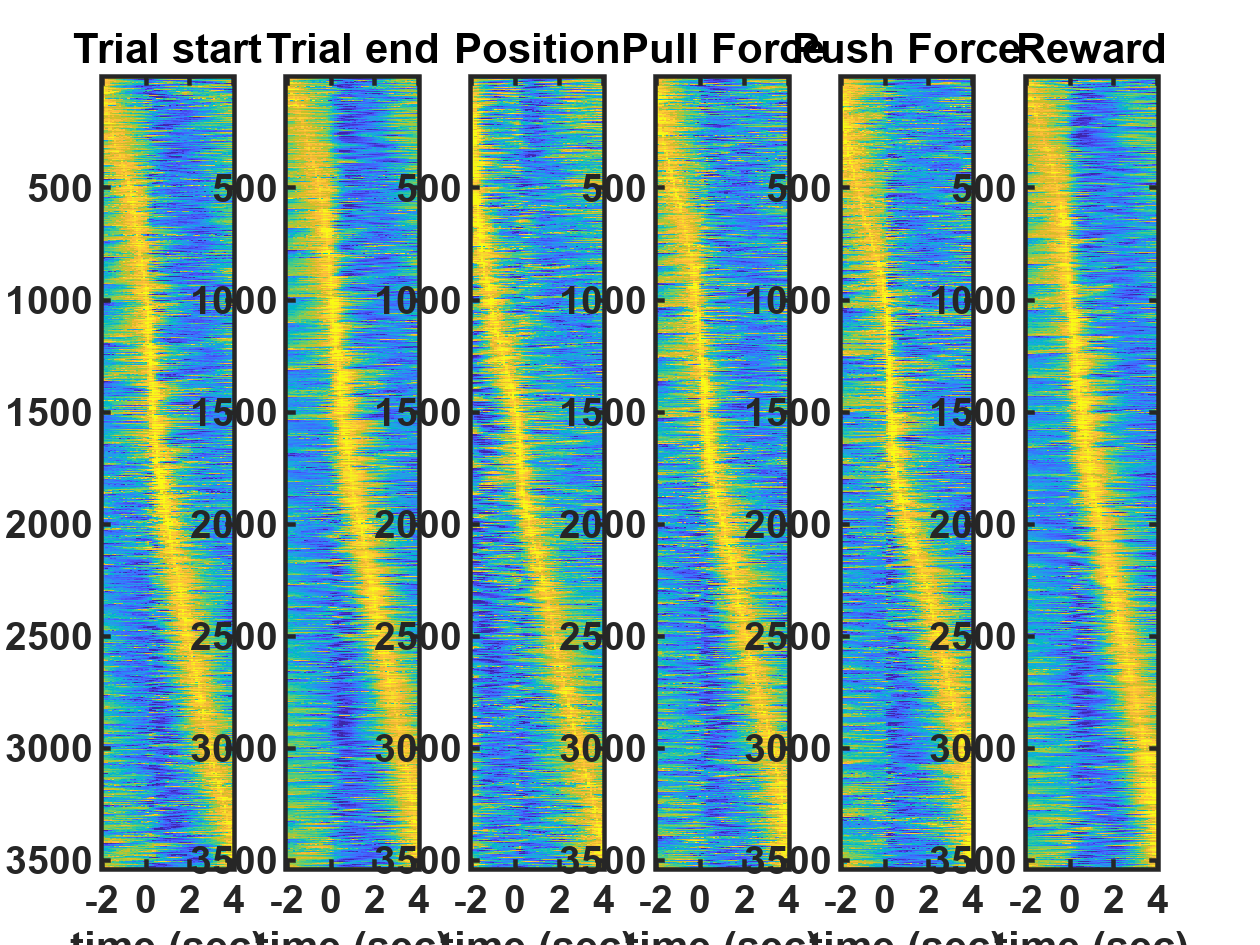

% plot layer specific eta by multiple plane figure
if strcmp(categorize, 'layer') == 1
    if norm == 1
        climit = [0 1];
    elseif norm == 2 | norm == 3 | norm == 4 | norm == 5
        climit = [-2 2];
    elseif norm == 6
        climit = [-4 4];
    else
        climit = [0 50];
    end
    
    layer23_act = {trial_start_act_layer23_conc, trial_end_act_layer23_conc, position_act_layer23_conc, force_act_layer23_conc, force_act2_layer23_conc, reward_act_layer23_conc};
    layer5_act  = {trial_start_act_layer5_conc, trial_end_act_layer5_conc, position_act_layer5_conc, force_act_layer5_conc, force_act2_layer5_conc, reward_act_layer5_conc};
    title_list = {'Trial start', 'Trial end', 'Position', 'Pull Force', 'Push Force', 'Reward'};
    figure
    set(gcf,'color','w');

    for i = 1:length(layer23_act) 
        subaxis(1,length(layer23_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer23_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer23_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     xlabel('time (sec)');
   
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_eta_activity_heatmap.png'];
    filename = [output_dir 'layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
    
    figure
    set(gcf,'color','w');
    for i = 1:length(layer5_act) 
        subaxis(1,length(layer5_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer5_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer5_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     ylabel('cell');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_eta_activity_heatmap.png'];
    filename = [output_dir 'layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    close all;
end

        3538



        3538



        8566



        8566



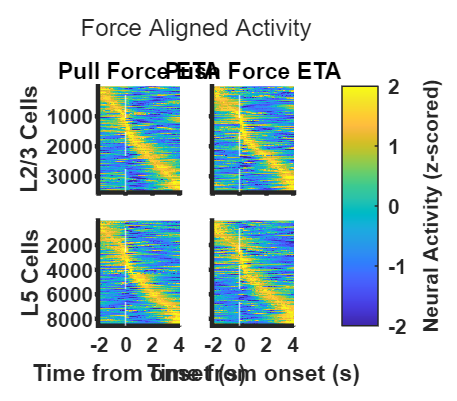

Plot saved to C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1369_rbp4c1377_rbp4c1379_rbp4c1384_norm2_inside_trial_eta2/force_activity_heatmap.svg


       12104



  221.1250



  535.3750



% plot for Cosyne 2026 abstract 
if strcmp(categorize, 'layer') == 1
    if norm == 1
        climit = [0 1];
    elseif norm == 2 | norm == 3 | norm == 4 | norm == 5
        climit = [-2 2];
    elseif norm == 6
        climit = [-4 4];
    else
        climit = [0 50];
    end
    
    layer23_act = {trial_start_act_layer23_conc, trial_end_act_layer23_conc, position_act_layer23_conc, force_act_layer23_conc, force_act2_layer23_conc, reward_act_layer23_conc};
    layer5_act  = {trial_start_act_layer5_conc, trial_end_act_layer5_conc, position_act_layer5_conc, force_act_layer5_conc, force_act2_layer5_conc, reward_act_layer5_conc};
    
    % --- プロットの開始 ---
    fig = figure('Position', [10, 10, 400, 350]);
    set(gcf, 'color', 'w'); % 背景を白に
    
    % 2x2のレイアウトを作成
    t = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(t, 'Force Aligned Activity', 'FontSize', 8);
    
    % X軸（時間）を定義
    x_time = -before_event : 0.1 : after_event;
    
    %% --- 1. L2/3 Pull Force ---
    ax1 = nexttile;
    imagesc(x_time, 1:size(layer23_act{4}, 1), layer23_act{4}, climit);
    disp(size(layer23_act{4}, 1))
    hold on;
    xline(0, 'w--', 'LineWidth', 0.5); % Time=0に白い縦の点線
    hold off;
    title('Pull Force ETA'); % ★ タイトルを変更
    ylabel('L2/3 Cells');
    
    %% --- 2. L2/3 Push Force ---
    ax2 = nexttile;
    imagesc(x_time, 1:size(layer23_act{5}, 1), layer23_act{5}, climit);
    disp(size(layer23_act{5}, 1))
    hold on;
    xline(0, 'w--', 'LineWidth', 0.5);
    hold off;
    title('Push Force ETA'); % ★ タイトルを変更
    
    %% --- 3. L5 Pull Force ---
    ax3 = nexttile;
    imagesc(x_time, 1:size(layer5_act{4}, 1), layer5_act{4}, climit);
    disp(size(layer5_act{4}, 1))
    hold on;
    xline(0, 'w--', 'LineWidth', 0.5);
    hold off;
    ylabel('L5 Cells');
    xlabel('Time from onset (s)');
    
    %% --- 4. L5 Push Force ---
    ax4 = nexttile;
    imagesc(x_time, 1:size(layer5_act{5}, 1), layer5_act{5}, climit);
    disp(size(layer5_act{5}, 1))
    hold on;
    xline(0, 'w--', 'LineWidth', 0.5);
    hold off;
    xlabel('Time from onset (s)');
    
    %% --- スタイルの適用 ---
    all_axes = [ax1, ax2, ax3, ax4];
    for i = 1:length(all_axes)
        set(all_axes(i), ...
            'box', 'off', ...
            'TickDir', 'out', ...
            'FontSize', 7);
    end
    set([ax1, ax2], 'XTickLabel', []);
    set([ax2, ax4], 'YTickLabel', []);
    
    %% --- カラーバーの調整 ---
    cb = colorbar(ax4);
    cb.Layout.Tile = 'east';
    cb.Label.String = 'Neural Activity (z-scored)';
    cb.FontSize = 7;
    
    % ★ カラーバーを小さくする
    % カラーバーの位置 [left, bottom, width, height] を取得
    original_pos = cb.Position;
    % 幅を元の50%に設定して、見た目を細くする
    cb.Position = [original_pos(1), original_pos(2), original_pos(3) * 0.5, original_pos(4)];
    
    %% --- SVG形式で保存 ---
    filename = [output_dir 'force_activity_heatmap.svg'];
    print(gcf, filename, '-dsvg', '-r300');
    
    fprintf('Plot saved to %s\n', filename);
    disp(size(layer23_act{5}, 1)+size(layer5_act{5}, 1))
    disp(size(layer23_act{5}, 1)/16)
    disp(size(layer5_act{5}, 1)/16)
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer23_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer23_cells{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;           
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer23_eta_activity_heatmap.png'];
    filename = [output_dir 'pull_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_act_layer23_cells{i};
        data = data(~any(isnan(data), 2), :);
        z = zscore(data, 0, 1); % 列方向に Zスコアを計算
        data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去
 
        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);      
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end      
        hold off;
        axis tight;  
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
        
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer23_eta_activity.png'];
    filename = [output_dir  'pull_layer23_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer5_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);        
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer5_cells{i},1),image,clims);
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;          
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer5_eta_activity_heatmap.png'];
    filename = [output_dir 'pull_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_act_layer5_cells{i};
        data = data(~any(isnan(data), 2), :);
        z = zscore(data, 0, 1); % 列方向に Zスコアを計算
        data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);              
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end       
        hold off;
        axis tight;          
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end     
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer5_eta_activity.png'];
    filename = [output_dir 'pull_layer5_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data23 = pull_act_layer23_cells{i};
        data23 = data23(~any(isnan(data23), 2), :);
        data5 = pull_act_layer5_cells{i};
        data5 = data5(~any(isnan(data5), 2), :);        
        z23 = zscore(data23, 0, 1); z5 = zscore(data5, 0, 1);% 列方向に Zスコアを計算
        data23 = data23(max(abs(z23), [], 2) < 10, :); data5 = data5(max(abs(z5), [], 2) < 10, :); % Zスコアが100以上の行を除去

        % mean_values = mean(data, 1);
        % std_values = std(data, 0, 1);              
        mean_values23 = mean(data23, 1);
        std_values23 = std(data23, 0, 1);        
        mean_values5 = mean(data5, 1);
        std_values5 = std(data5, 0, 1);
        x = -before_event:0.1:after_event;

        hold on;        
        fill([x, fliplr(x)], [mean_values23 + std_values23, fliplr(mean_values23 - std_values23)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values23, 'g', 'LineWidth', 1.5); 
        fill([x, fliplr(x)], [mean_values5 + std_values5, fliplr(mean_values5 - std_values5)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values5, 'b', 'LineWidth', 1.5);         
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end        
        hold off;
        axis tight;  
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end      
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer235_eta_activity.png'];
    filename = [output_dir 'pull_layer235_eta_activity.png'];
    saveas(gcf,filename);
    close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    title_list = {'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};

    figure('Position', [100, 100, 1600, 600]);
    for i = 1:4
        subaxis(1,4,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.08);
        % NaNを含む行を削除
        if i == 1
            data1 = pull_act_layer23_cells{1}; data2 = pull_act_layer23_cells{2};
            data11 = pull_act_layer5_cells{1}; data21 = pull_act_layer5_cells{2};            
        elseif i == 4
            data1 = pull_act_layer23_cells{3}; data2 = pull_act_layer23_cells{5};   
            data3 = pull_act_layer23_cells{4}; data4 = pull_act_layer23_cells{6};
            data11 = pull_act_layer5_cells{3}; data21 = pull_act_layer5_cells{5};   
            data31 = pull_act_layer5_cells{4}; data41 = pull_act_layer5_cells{6};            
        else
            data1 = pull_act_layer23_cells{i+1}; data2 = pull_act_layer23_cells{i+3};
            data11 = pull_act_layer5_cells{i+1}; data21 = pull_act_layer5_cells{i+3};            
        end
        data1 = data1(~any(isnan(data1), 2), :); data2 = data2(~any(isnan(data2), 2), :);
        data11 = data11(~any(isnan(data11), 2), :); data21 = data21(~any(isnan(data21), 2), :);         
        z1 = zscore(data1, 0, 1); z2 = zscore(data2, 0, 1); % 列方向に Zスコアを計算
        data1 = data1(max(abs(z1), [], 2) < 10, :); data2 = data2(max(abs(z2), [], 2) < 10, :); % Zスコアが100以上の行を除去
        z11 = zscore(data11, 0, 1); z21 = zscore(data21, 0, 1); % 列方向に Zスコアを計算
        data11 = data11(max(abs(z11), [], 2) < 10, :); data21 = data21(max(abs(z21), [], 2) < 10, :); % Zスコアが100以上の行を除去
        mean_values1 = mean(data1, 1); mean_values2 = mean(data2, 1);
        std_values1 = std(data1, 0, 1); std_values2 = std(data2, 1);
        mean_values11 = mean(data11, 1); mean_values21 = mean(data21, 1);
        std_values11 = std(data11, 0, 1); std_values21 = std(data21, 1);         
        if i == 4
            data3 = data3(~any(isnan(data3), 2), :); data4 = data4(~any(isnan(data4), 2), :); 
            data31 = data31(~any(isnan(data31), 2), :); data41 = data41(~any(isnan(data41), 2), :);             
            z3 = zscore(data3, 0, 1); z4 = zscore(data4, 0, 1); % 列方向に Zスコアを計算
            data3 = data3(max(abs(z3), [], 2) < 10, :); data4 = data4(max(abs(z4), [], 2) < 10, :); % Zスコアが100以上の行を除去
            z31 = zscore(data31, 0, 1); z41 = zscore(data41, 0, 1); % 列方向に Zスコアを計算
            data31 = data31(max(abs(z31), [], 2) < 10, :); data41 = data41(max(abs(z41), [], 2) < 10, :); % Zスコアが100以上の行を除去
            mean_values31 = mean(data31, 1); mean_values41 = mean(data41, 1);
            std_values31 = std(data31, 0, 1); std_values41 = std(data41, 1);             
        end
        x = -before_event:0.1:after_event;
      
        if i == 1
            hold on;
            plot(x, mean_values1,  'Color', [0 0.5 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0.5 1 0], 'LineWidth', 1.5); 
            plot(x, mean_values11, 'b', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'c', 'LineWidth', 1.5);             
        elseif i == 2
            hold on;
            plot(x, mean_values1, 'Color', [0 0.5 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0 0.5 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values11, 'b', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'b', 'LineWidth', 1.5,'LineStyle', ':');            
        elseif i == 3
            hold on;
            plot(x, mean_values1, 'Color', [0.5 1 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0.5 1 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values11, 'c', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'c', 'LineWidth', 1.5,'LineStyle', ':');               
        else
            hold on;
            plot(x, mean_values1, 'Color', [0 0.5 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0 0.5 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values3, 'Color', [0.5 1 0], 'LineWidth', 1.5); 
            plot(x, mean_values4, 'Color', [0.5 1 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values11, 'b', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values31, 'c', 'LineWidth', 1.5); 
            plot(x, mean_values41, 'c', 'LineWidth', 1.5,'LineStyle', ':');             
        end
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 2]); %ylim([-1 6]); %
        end
    end
        
        % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer235_eta_activity_compare.png'];
        filename = [output_dir 'pull_layer235_eta_activity_compare.png'];
        saveas(gcf,filename);
    close all;
end

close all;close(gcf);

% 階層的クラスタリングの実施

if Kota_alignment == 1
    % NaNを含む行を削除
    data = pull_actss{length(AlinmentTimingCells)+1};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_hierarchical_clustering_dendrogram.png'];
    filename = [output_dir 'hierarchical_clustering_dendrogram.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_elbow.png'];
    filename = [output_dir 'elbow.png'];
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_eta_heatmap2.png'];
    filename = [output_dir 'eta_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
    close(gcf);
end

% plot clustered ETA neural activity
if Kota_alignment == 1
    num_clusters = 5; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    all_cluster_labels = cluster_labels;
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end

    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};

    fig_y = 600*num_clusters;
    % figure('Position', [100, 100, fig_y, 2400]);
    figure('Position', [100, 100, 2400, fig_y]);    
    for i = 1:length(AlinmentTimingCells)
        % NaNを含む行を削除
        i_data = pull_actss{i};
        % i_data = i_data(~any(isnan(i_data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters   
            % subaxis(num_clusters,length(AlinmentTimingCells),(i-1)*length(AlinmentTimingCells)+cluster_num, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            subaxis(num_clusters,length(AlinmentTimingCells),i+length(AlinmentTimingCells)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
            z = zscore(cluster_data, 0, 1); % 列方向に Zスコアを計算
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'b', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 24]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_eta_activity.png'];
    filename = [output_dir 'clustered_pull_eta_activity.png'];
    saveas(gcf,filename);
    close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};
    fig_y = 400*num_clusters;
    % fig_y = 600*num_clusters;
    figure('Position', [100, 100, fig_y, 2400]);
    % figure('Position', [100, 100, 1600, fig_y]);
    for i = 1:4
        % NaNを含む行を削除
        if i == 1
            data1 = pull_actss{1}; data2 = pull_actss{2};
        elseif i == 4
            data1 = pull_actss{3}; data2 = pull_actss{5};   
            data3 = pull_actss{4}; data4 = pull_actss{6};
        else
            data1 = pull_actss{i+1}; data2 = pull_actss{i+3};
        end        
        % i_data = pull_actss{i};
        % i_data = i_data(~any(isnan(data), 2), :);

        for cluster_num = 1:num_clusters
            subaxis(4,num_clusters,(i-1)*num_clusters+cluster_num, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);            
            % subaxis(num_clusters,4,i+4*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data1 = data1(cluster_labels == cluster_num, :); cluster_data2 = data2(cluster_labels == cluster_num, :);
            cluster_data1 = cluster_data1(~any(isnan(cluster_data1), 2), :); cluster_data2 = cluster_data2(~any(isnan(cluster_data2), 2), :);
            z1 = zscore(cluster_data1, 0, 1); z2 = zscore(cluster_data2, 0, 1); % 列方向に Zスコアを計算
            cluster_data1 = cluster_data1(max(abs(z1), [], 2) < 10, :); cluster_data2 = cluster_data2(max(abs(z2), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values1 = mean(cluster_data1, 1); mean_values2 = mean(cluster_data2, 1);
            std_values1 = std(cluster_data1, 0, 1); std_values2 = std(cluster_data2, 0, 1);
            if i == 4
                cluster_data3 = data3(cluster_labels == cluster_num, :); cluster_data4 = data4(cluster_labels == cluster_num, :);
                cluster_data3 = cluster_data3(~any(isnan(cluster_data3), 2), :); cluster_data4 = cluster_data4(~any(isnan(cluster_data4), 2), :);   
                z3 = zscore(cluster_data3, 0, 1); z4 = zscore(cluster_data4, 0, 1); % 列方向に Zスコアを計算
                cluster_data3 = cluster_data3(max(abs(z3), [], 2) < 10, :); cluster_data4 = cluster_data4(max(abs(z4), [], 2) < 10, :); % Zスコアが100以上の行を除去
                mean_values3 = mean(cluster_data3, 1); mean_values4 = mean(cluster_data4, 1);
                std_values3 = std(cluster_data3, 0, 1); std_values4 = std(cluster_data4, 0, 1);           
            end            
            x = -before_event:0.1:after_event;
          
            % fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            % hold on;
            % plot(x, mean_values, 'b', 'LineWidth', 1.5); 
            if i == 1
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
                plot(x, mean_values2, 'Color', [0 0.8 1.0], 'LineWidth', L_width);               
                % plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
                % % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                % plot(x, mean_values2, 'c', 'LineWidth', 1.5); 
            elseif i == 2
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
                % plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values2, 'Color', [0 0 0.5], 'LineWidth', L_width,'LineStyle', ':');
                % plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
            elseif i == 3
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'Color', [0 0.8 1.0], 'LineWidth', L_width); 
                % plot(x, mean_values1, 'c', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values2, 'Color', [0 0.8 1.0], 'LineWidth', L_width,'LineStyle', ':'); 
                % plot(x, mean_values2, 'c', 'LineWidth', 1.5,'LineStyle', ':');             
            else
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
                % plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values2, 'Color', [0 0 0.5], 'LineWidth', L_width,'LineStyle', ':');                
                plot(x, mean_values3, 'Color', [0 0.8 1.0], 'LineWidth', L_width); 
                % plot(x, mean_values1, 'c', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values4, 'Color', [0 0.8 1.0], 'LineWidth', L_width,'LineStyle', ':');                 
                % plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
                % % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                % plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
                % % fill([x, fliplr(x)], [mean_values3 + std_values3, fliplr(mean_values3 - std_values3)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                % plot(x, mean_values3, 'c', 'LineWidth', 1.5); 
                % % fill([x, fliplr(x)], [mean_values4 + std_values4, fliplr(mean_values4 - std_values4)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                % plot(x, mean_values4, 'c', 'LineWidth', 1.5,'LineStyle', ':');            
            end            
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', L_width); % x=0 に赤い縦線を描画
            end
            hold off;
            if cluster_num == 1
            % if i == 1
                ylabel('normalized activity');
            end
            if i == 4
            % if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            % if cluster_num == 1
            %     title(title_list{i});
            % end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 12]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_eta_activity_compare.png'];
    filename = [output_dir 'clustered_pull_eta_activity_compare.png'];
    saveas(gcf,filename);
    % close all;
end

% Layer23 階層的クラスタリングの実施

if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    % NaNを含む行を削除
    data = pull_act_layer23_cells{length(AlinmentTimingCells)+1};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_hierarchical_clustering_dendrogram.png'];
    filename = [output_dir 'layer23_hierarchical_clustering_dendrogram.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_elbow.png'];
    filename = [output_dir 'layer23_elbow.png']; 
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_eta_heatmap2.png'];
    filename = [output_dir 'layer23_eta_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
end

% plot clustered ETA neural activity
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    num_clusters = 4; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end

    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};

    fig_y = 600*num_clusters;
    figure('Position', [100, 100, 2400, fig_y]);
    for i = 1:length(AlinmentTimingCells)
        % NaNを含む行を削除
        i_data = pull_act_layer23_cells{i};
        i_data = i_data(~any(isnan(data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters
            subaxis(num_clusters,length(AlinmentTimingCells),i+length(AlinmentTimingCells)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
            z = zscore(cluster_data, 0, 1); % 列方向に Zスコアを計算
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'g', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 24]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_layer23_eta_activity.png'];
    filename = [output_dir 'clustered_pull_layer23_eta_activity.png'];
    saveas(gcf,filename);
    close all;
end

% Layer5 階層的クラスタリングの実施

if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    % NaNを含む行を削除
    data = pull_act_layer5_cells{length(AlinmentTimingCells)+1};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_hierarchical_clustering_dendrogram.png'];
    filename = [output_dir 'layer5_hierarchical_clustering_dendrogram.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_elbow.png'];
    filename = [output_dir 'layer5_elbow.png'];
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_eta_heatmap2.png'];
    filename = [output_dir 'layer5_eta_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
end

% plot clustered ETA neural activity
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    num_clusters = 3; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end

    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};

    fig_y = 600*num_clusters;
    figure('Position', [100, 100, 2400, fig_y]);
    for i = 1:length(AlinmentTimingCells)
        % NaNを含む行を削除
        i_data = pull_act_layer5_cells{i};
        i_data = i_data(~any(isnan(data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters
            subaxis(num_clusters,length(AlinmentTimingCells),i+length(AlinmentTimingCells)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
             z = zscore(cluster_data, 0, 1); % 列方向に Zスコアを計算
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'b', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 24]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_layer5_eta_activity.png'];
    filename = [output_dir 'clustered_pull_layer5_eta_activity.png'];
    saveas(gcf,filename);
    close all;
end

% check the ratio of cells in each layer in each cluster
% all_cluster_labels
% pointAreas_conc
if Kota_alignment == 1
    unique_pairs = unique([all_cluster_labels, pointAreas_conc], 'rows');
    counts = zeros(size(unique_pairs, 1), 1);
    
    for i = 1:size(unique_pairs, 1)
        counts(i) = sum(ismember([all_cluster_labels, pointAreas_conc], unique_pairs(i, :), 'rows'));
    end
    
    for i = 1:size(unique_pairs, 1)
        fprintf('Pair (%d, %d): %d times\n', unique_pairs(i, 1), unique_pairs(i, 2), counts(i));
    end
end

if Kota_alignment == 1
    % ユニークな要素を見つける
    unique_list2 = unique(pointAreas_conc);
    
    % Figureの作成
    figure('Position', [100, 100, 2400, 600]);
    
    % 各カテゴリーごとにプロット
    num_categories = length(unique_list2);
    for i = 1:num_categories
        category = unique_list2(i);
        indices = pointAreas_conc == category;
        subset_list1 = all_cluster_labels(indices);
        
        % List1のカテゴリーの割合を計算
        unique_subset_list1 = unique(subset_list1);
        counts = histc(subset_list1, unique_subset_list1);
        percentages = counts / sum(counts) * 100;
        
        % 円グラフをプロット
        subplot(1, num_categories, i);
        % pie(percentages, arrayfun(@num2str, unique_subset_list1, 'UniformOutput', false));
        pie(percentages, arrayfun(@(x) [num2str(counts(x == unique_subset_list1)) ' - ' num2str(round(percentages(x == unique_subset_list1), 2)) '%'], unique_subset_list1, 'UniformOutput', false));
        legend(arrayfun(@num2str, unique_subset_list1, 'UniformOutput', false), 'Location', 'southoutside', 'Orientation', 'horizontal');    
        if category == 0
            title(['Layer 5']);
        else
            title(['Layer 23']);
        end
    end
    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer235_cluster_percentage.png'];
     filename = [output_dir 'layer235_cluster_percentage.png'];
    saveas(gcf,filename);
end

% plot ratio of significantly activated cells
if norm == 3 & Kota_alignment == 1
    %Actual resistance cell ratio
    % テキストファイルのオープン
    txtname = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_sig_cell_ratio.txt'];
    fileID = fopen(txtname, 'w');
    % Figureの作成
    figure('Position', [100, 100, 2400, 600]);
    legend({'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'}, 'Location', 'eastoutside'); 
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    h_sig_idxs = pull_sig_cell_idxs{1};
    l_sig_idxs = pull_sig_cell_idxs{2};
    for i_sig = 1:size(pull_sig_cell_idxs{1},1)
        h_sig_idx = h_sig_idxs(i_sig,:);
        l_sig_idx = l_sig_idxs(i_sig,:);
        
        % 組み合わせの個数をカウント
        both_one = sum(h_sig_idx == 1 & l_sig_idx == 1);
        h_one_l_zero = sum(h_sig_idx == 1 & l_sig_idx == 0);
        h_zero_l_one = sum(h_sig_idx == 0 & l_sig_idx == 1);
        both_zero = sum(h_sig_idx == 0 & l_sig_idx == 0);
               
        % 円グラフ用のデータ
        total = length(h_sig_idx);
        data = [both_one, h_one_l_zero, h_zero_l_one, both_zero]; %/length(h_sig_idx)*100;
        % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};

        % % 円グラフ用のラベル
        % labels = {
        %     ['Heavy and light pull: ', num2str(both_one), ' (', num2str(both_one / total * 100, '%.2f'), '%)'], ...
        %     ['Heavy pull: ', num2str(h_one_l_zero), ' (', num2str(h_one_l_zero / total * 100, '%.2f'), '%)'], ...
        %     ['Light pull: ', num2str(h_zero_l_one), ' (', num2str(h_zero_l_one / total * 100, '%.2f'), '%)'], ...
        %     ['Neither: ', num2str(both_zero), ' (', num2str(both_zero / total * 100, '%.2f'), '%)']
        % };
        % カウントの結果をテキストファイルに書き込む
        fprintf(fileID, 'Signal %d\n', i_sig);
        fprintf(fileID, 'Heavy and light pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
        fprintf(fileID, 'Heavy pull: %d (%.2f%%)\n', h_one_l_zero, h_one_l_zero / total * 100);
        fprintf(fileID, 'Light pull: %d (%.2f%%)\n', h_zero_l_one, h_zero_l_one / total * 100);
        fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
        fprintf(fileID, '\n');        
        
        % 円グラフのプロット
        subplot(1, size(pull_sig_cell_idxs{1},1), i_sig);      
        pie(data, {'', '', '', ''});
        colormap([0 0 0; 0 0 1; 0 1 1; 0.5 0.5 0.5]); % 黒、濃い青、水色、灰色
        title(title_list{i_sig});        
    end   
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_actual_res_sig_cell_ratio.png'];
    filename = [output_dir 'actual_res_sig_cell_ratio.png'];
    saveas(gcf,filename);
    % Resistance Expected vs Unexpected cell ratio
    % Figureの作成
    figure('Position', [100, 100, 2400, 600]);
    legend({'Expected and unexpected pull', 'Expected pull', 'Unexpected pull', 'Neither'}, 'Location', 'eastoutside');     
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    e_sig_idxs = pull_sig_cell_idxs{3} | pull_sig_cell_idxs{4};
    u_sig_idxs = pull_sig_cell_idxs{5} | pull_sig_cell_idxs{6};
    for i_sig = 1:size(pull_sig_cell_idxs{1},1)
        e_sig_idx = e_sig_idxs(i_sig,:);
        u_sig_idx = u_sig_idxs(i_sig,:);
        
        % 組み合わせの個数をカウント
        both_one = sum(e_sig_idx == 1 & u_sig_idx == 1);
        e_one_u_zero = sum(e_sig_idx == 1 & u_sig_idx == 0);
        e_zero_u_one = sum(e_sig_idx == 0 & u_sig_idx == 1);
        both_zero = sum(e_sig_idx == 0 & u_sig_idx == 0);
        
        % 円グラフ用のデータ
        total = length(e_sig_idx);
        data = [both_one, e_one_u_zero, e_zero_u_one, both_zero]; %/length(e_sig_idx)*100;
        % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};
    
        % カウントの結果をテキストファイルに書き込む
        fprintf(fileID, 'Signal %d\n', i_sig);
        fprintf(fileID, 'Expected and unexpected pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
        fprintf(fileID, 'Expected pull: %d (%.2f%%)\n', e_one_u_zero, e_one_u_zero / total * 100);
        fprintf(fileID, 'Unexpected pull: %d (%.2f%%)\n', e_zero_u_one, e_zero_u_one / total * 100);
        fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
        fprintf(fileID, '\n');          
        
        % 円グラフのプロット
        subplot(1, size(pull_sig_cell_idxs{1},1), i_sig);      
        pie(data, {'', '', '', ''}); 
        colormap([0 0 0; 0 0.5 0; 0.5 1 0; 0.5 0.5 0.5]); % 黒、緑、淡い緑、灰色
        title(title_list{i_sig});
    end    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_expect_res_sig_cell_ratio.png'];
    filename = [output_dir 'expect_res_sig_cell_ratio.png'];
    saveas(gcf,filename);

    % テキストファイルのクローズ
    fclose(fileID);    
end

% plot ratio of significantly activated cells
if norm == 3 & strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    %Actual resistance cell ratio
    % ユニークな要素を見つける
    unique_list2 = unique(pointAreas_conc);
    % 各カテゴリーごとにプロット
    num_categories = length(unique_list2);  
    % テキストファイルのオープン
    txtname = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer_sig_cell_ratio.txt'];
    fileID = fopen(txtname, 'w');    
    % Figureの作成
    figure('Position', [100, 100, 2400, 1200]);
    legend({'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'}, 'Location', 'eastoutside');     
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    h_sig_idxs = pull_sig_cell_idxs{1};h_sig_idxs_ori = pull_sig_cell_idxs{1};
    l_sig_idxs = pull_sig_cell_idxs{2};l_sig_idxs_ori = pull_sig_cell_idxs{2};
    for i = 1:num_categories
        category = unique_list2(i);
        indices = pointAreas_conc == category;
        h_sig_idxs = h_sig_idxs_ori(:,indices);
        l_sig_idxs = l_sig_idxs_ori(:,indices);
        for i_sig = 1:size(pull_sig_cell_idxs{1},1)
            h_sig_idx = h_sig_idxs(i_sig,:);
            l_sig_idx = l_sig_idxs(i_sig,:);
            
            % 組み合わせの個数をカウント
            both_one = sum(h_sig_idx == 1 & l_sig_idx == 1);
            h_one_l_zero = sum(h_sig_idx == 1 & l_sig_idx == 0);
            h_zero_l_one = sum(h_sig_idx == 0 & l_sig_idx == 1);
            both_zero = sum(h_sig_idx == 0 & l_sig_idx == 0);
   
            % 円グラフ用のデータ
            total = length(h_sig_idx);
            data = [both_one, h_one_l_zero, h_zero_l_one, both_zero]; %/length(h_sig_idx)*100;
            % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};
    
            % カウントの結果をテキストファイルに書き込む
            fprintf(fileID, 'Layer %d\n', i);
            fprintf(fileID, 'Signal %d\n', i_sig);
            fprintf(fileID, 'Heavy and light pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
            fprintf(fileID, 'Heavy pull: %d (%.2f%%)\n', h_one_l_zero, h_one_l_zero / total * 100);
            fprintf(fileID, 'Light pull: %d (%.2f%%)\n', h_zero_l_one, h_zero_l_one / total * 100);
            fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
            fprintf(fileID, '\n');              
            
            % 円グラフのプロット
            subplot(2, size(pull_sig_cell_idxs{1},1), (i-1)*7+i_sig);      
            pie(data, {'', '', '', ''});           
            colormap([0 0 0; 0 0 1; 0 1 1; 0.5 0.5 0.5]); % 黒、濃い青、水色、灰色
            % title(title_list{i_sig});
            if category == 0
                title(['Layer 5',title_list{i_sig}]);
            else
                title(['Layer 23',title_list{i_sig}]);
            end
        end
    end
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_actual_res_layer_sig_cell_ratio.png'];
    filename = [output_dir  'actual_res_layer_sig_cell_ratio.png'];
    saveas(gcf,filename);    
    % Resistance Expected vs Unexpected cell ratio
    % Figureの作成
    figure('Position', [100, 100, 2400, 1200]);
    legend({'Expected and unexpected pull', 'Expected pull', 'Unexpected pull', 'Neither'}, 'Location', 'eastoutside');     
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    e_sig_idxs = pull_sig_cell_idxs{3} | pull_sig_cell_idxs{4};e_sig_idxs_ori = pull_sig_cell_idxs{3} | pull_sig_cell_idxs{4};
    u_sig_idxs = pull_sig_cell_idxs{5} | pull_sig_cell_idxs{6};u_sig_idxs_ori = pull_sig_cell_idxs{5} | pull_sig_cell_idxs{6};
    for i = 1:num_categories
        category = unique_list2(i);
        indices = pointAreas_conc == category;
        e_sig_idxs = e_sig_idxs_ori(:,indices);
        u_sig_idxs = u_sig_idxs_ori(:,indices);
        for i_sig = 1:size(pull_sig_cell_idxs{1},1)
            e_sig_idx = e_sig_idxs(i_sig,:);
            u_sig_idx = u_sig_idxs(i_sig,:);
            
            % 組み合わせの個数をカウント
            both_one = sum(e_sig_idx == 1 & u_sig_idx == 1);
            e_one_u_zero = sum(e_sig_idx == 1 & u_sig_idx == 0);
            e_zero_u_one = sum(e_sig_idx == 0 & u_sig_idx == 1);
            both_zero = sum(e_sig_idx == 0 & u_sig_idx == 0);
            
            % 円グラフ用のデータ
            total = length(e_sig_idx);
            data = [both_one, e_one_u_zero, e_zero_u_one, both_zero]; %/length(e_sig_idx)*100;
            % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};
        
            % 円グラフ用のラベル
            labels = {
                ['Expected and unexpected pull: ', num2str(both_one), ' (', num2str(both_one / total * 100, '%.2f'), '%)'], ...
                ['Expected pull: ', num2str(e_one_u_zero), ' (', num2str(e_one_u_zero / total * 100, '%.2f'), '%)'], ...
                ['Unexpected pull: ', num2str(e_zero_u_one), ' (', num2str(e_zero_u_one / total * 100, '%.2f'), '%)'], ...
                ['Neither: ', num2str(both_zero), ' (', num2str(both_zero / total * 100, '%.2f'), '%)']
            };
            % カウントの結果をテキストファイルに書き込む
            fprintf(fileID, 'Layer %d\n', i);            
            fprintf(fileID, 'Signal %d\n', i_sig);
            fprintf(fileID, 'Expected and unexpected pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
            fprintf(fileID, 'Expected pull: %d (%.2f%%)\n', e_one_u_zero, e_one_u_zero / total * 100);
            fprintf(fileID, 'Unexpected pull: %d (%.2f%%)\n', e_zero_u_one, e_zero_u_one / total * 100);
            fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
            fprintf(fileID, '\n');              
            
            % 円グラフのプロット
            subplot(2, size(pull_sig_cell_idxs{1},1), (i-1)*7+i_sig);      
            pie(data, {'', '', '', ''});         
            colormap([0 0 0; 0 0.5 0; 0.5 1 0; 0.5 0.5 0.5]); % 黒、緑、淡い緑、灰色
            % title(title_list{i_sig});
            if category == 0
                title(['Layer 5',title_list{i_sig}]);
            else
                title(['Layer 23',title_list{i_sig}]);
            end
        end
    end
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_expect_res_layer_sig_cell_ratio.png'];
    filename = [output_dir '_expect_res_layer_sig_cell_ratio.png'];
    saveas(gcf,filename);   
    % テキストファイルのクローズ
    fclose(fileID); 
end

% scatter plot of peak after pull in each conditioins
if Kota_alignment == 1
    % 各ペアのスキャタープロット
    pairs = {[3, 5], [4, 6], [5, 6]};
    titles = {'pull_acts{3} vs pull_acts{5}', 'pull_acts{4} vs pull_acts{6}', 'pull_acts{5} vs pull_acts{6}'};
    
    figure('Position', [100, 100, 1800, 600]);
    
    % 全データの最大値と最小値を計算
    all_data = [];
    for i = 1:length(pairs)
        idx1 = pairs{i}(1);
        idx2 = pairs{i}(2);
        x_data = max(pull_actss{idx1}(:, 21:41), [], 2);
        y_data = max(pull_actss{idx2}(:, 21:41), [], 2);
        all_data = [all_data; x_data; y_data];
    end
    data_min = min(all_data);
    data_max = max(all_data);

    % 結果を保存するためのファイルを開く
    results_file = fopen([output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_results.txt'], 'w');
       
    for i = 1:length(pairs)
        idx1 = pairs{i}(1);
        idx2 = pairs{i}(2);
    
        % 21列目から41列目の最大値を計算
        x_data = max(pull_actss{idx1}(:, 21:41), [], 2);
        y_data = max(pull_actss{idx2}(:, 21:41), [], 2);
        
        valid_idx = ~isnan(x_data) & ~isnan(y_data);
        x_data = x_data(valid_idx);
        y_data = y_data(valid_idx);        

        % スキャタープロット
        subplot(1, 3, i);
        scatter(x_data, y_data, 'filled');
        hold on;
        
        % x=y, x=0, y=0の黒い点線を追加
        plot([data_min data_max], [data_min data_max], 'k--');
        plot([0 0], [data_min data_max], 'k--');
        plot([data_min data_max], [0 0], 'k--');
        
        % 相関を計算
        [R, P] = corr(x_data, y_data);

        % 相関の結果をテキストファイルに保存
        fprintf(results_file, '%s\n', titles{i});
        fprintf(results_file, 'Correlation: r = %.2f, p = %.2e\n', R, P);        
        
        % % 相関の結果をプロットに表示
        % text(data_min + (data_max-data_min)*0.05, data_max - (data_max-data_min)*0.1, ...
        %     sprintf('r = %.2f, p = %.2e', R, P), 'FontSize', 12);
        
        % x=y からのずれの統計的検定
        differences = y_data - x_data;
        mean(differences)
        [h, p_ttest, ci, stats] = ttest(differences);
        
        % 検定結果をテキストファイルに保存
        if h == 0
            test_result = 'No significant difference';
        else
            test_result = 'Significant difference';
        end        
        
        % text(data_min + (data_max-data_min)*0.05, data_max - (data_max-data_min)*0.2, ...
        %     sprintf('%s\np = %.2e', test_result, p_ttest), 'FontSize', 12);
        % 検定結果をテキストファイルに保存
        if h == 0
            test_result = 'No significant difference';
        else
            test_result = 'Significant difference';
        end        
        
        % x>y かつ x>1 の範囲にある点の数をカウント
        count_x_greater_y = sum(x_data > y_data & x_data > 1);
        % x<y かつ y>1 の範囲にある点の数をカウント
        count_y_greater_x = sum(x_data < y_data & y_data > 1);
        % 全体の点の数
        total_points = count_x_greater_y+count_y_greater_x;
        
        % 比の検定
        p0 = 0.5; % 比較する母比率
        phat = count_x_greater_y / total_points; % 観測された比率
        z = (phat - p0) / sqrt(p0 * (1 - p0) / total_points); % z値の計算
        p_value_proportion = 2 * (1 - normcdf(abs(z))); % 両側検定のp値
              
        
        % 結果をテキストファイルに保存
        fprintf(results_file, 'Points where x > y and x > 1: %d\n', count_x_greater_y);
        fprintf(results_file, 'Points where x < y and y > 1: %d\n\n', count_y_greater_x);
        fprintf(results_file, 'Proportion test for x > y and x > 1:\n');
        fprintf(results_file, 'Observed proportion: %.2f\n', phat);
        fprintf(results_file, 'p-value: %.2e\n\n', p_value_proportion);
        % % 線形回帰
        % coeffs = polyfit(x_data, y_data, 1);
        % y_fit = polyval(coeffs, [data_min data_max]);
        % plot([data_min data_max], y_fit, 'r-', 'LineWidth', 1.5);      
        
        xlabel(['pull\_acts{' num2str(idx1) '} max value']);
        ylabel(['pull\_acts{' num2str(idx2) '} max value']);
        title(titles{i});
        
        % X軸とY軸の範囲を設定
        xlim([data_min data_max]);
        ylim([data_min data_max]);
        
        hold off;
    end
    
    % グラフの保存
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_peak_after_pull_scatter.png'];
    filename = [output_dir 'peak_after_pull_scatter.png'];
    saveas(gcf,filename);  
end

%% ========================================================================
% Step 2: Task-variable encoding GLM
%
% State:
%   +0.5 : pullResistance > pushResistance
%   -0.5 : pullResistance < pushResistance
%
% Action:
%   -0.5 : Pull
%   +0.5 : Push
%
% RewardAmount:
%   Push : pushReward
%   Pull : 4 - pushReward
%
% Layer:
%   pointAreas_all_sessions == 1 : L2/3
%   pointAreas_all_sessions == 0 : L5
%
% Cell criterion:
%   regression p < 0.01
%
% Population significance:
%   trial-shuffle permutation test
%
% ========================================================================


%% ------------------------------------------------------------------------
% Parameters
% -------------------------------------------------------------------------

glm_reward_high_thr = 2.1;
glm_reward_low_thr  = 1.9;
glm_reward_sum      = 4;

glm_min_obs = 20;
glm_min_obs_per_condition = 3;

glm_cell_p_threshold = 0.01;

glm_n_permutations = 1000;
glm_population_alpha = 0.05;

rng(1);


%% ------------------------------------------------------------------------
% Analysis windows
% -------------------------------------------------------------------------

glm_windows = struct([]);

glm_windows(1).name    = 'PreAction';
glm_windows(1).start_s = -1.0;
glm_windows(1).end_s   =  0.0;

glm_windows(2).name    = 'EarlyPost';
glm_windows(2).start_s =  0.0;
glm_windows(2).end_s   =  1.0;

glm_windows(3).name    = 'LatePost';
glm_windows(3).start_s =  1.0;
glm_windows(3).end_s   =  2.0;

n_glm_windows = length(glm_windows);


%% ------------------------------------------------------------------------
% GLM terms
% -------------------------------------------------------------------------

glm_term_names = { ...
    'StateCode', ...
    'ActionCode', ...
    'RewardZ', ...
    'StateAction', ...
    'StateReward', ...
    'ActionReward', ...
    'StateActionReward', ...
    'TrialTrend'};

n_glm_terms = length(glm_term_names);

idx_reward              = 3;
idx_state_reward        = 5;
idx_action_reward       = 6;
idx_state_action_reward = 7;

effect_names = { ...
    'Reward', ...
    'StateReward', ...
    'ActionReward', ...
    'StateActionReward'};

effect_term_idx = [ ...
    idx_reward, ...
    idx_state_reward, ...
    idx_action_reward, ...
    idx_state_action_reward];

n_effects = length(effect_names);


%% ------------------------------------------------------------------------
% Output
% -------------------------------------------------------------------------

task_glm_results = cell(length(Animal), n_glm_windows);

% One row = one session x window x layer
task_glm_layer_summary_cell = {};

% One row = one session x window x effect
% Used for within-session L2/3 vs L5 comparison
task_glm_layer_comparison_cell = {};


%% ========================================================================
% Session loop
% ========================================================================

for i_animal = 1:length(Animal)

    fprintf('\n============================================================\n');
    fprintf('Session %d / %d | %s | %s\n', ...
        i_animal, length(Animal), ...
        string(Animal{i_animal}), string(Date{i_animal}));
    fprintf('============================================================\n');


    %% --------------------------------------------------------------------
    % Existing data
    % ---------------------------------------------------------------------

    neural_data = ...
        acc_neural_activity_data_all_sessions{i_animal};

    trial = trial_sessions{i_animal};

    pullResistance = ...
        pullResistance_sessions{i_animal};

    pushResistance = ...
        pushResistance_sessions{i_animal};

    pushReward = ...
        pushReward_sessions{i_animal};

    pull_event_idx = ...
        force_idx_sessions{i_animal}(:);

    push_event_idx = ...
        force_idx2_sessions{i_animal}(:);

    % Layer:
    % 1 = L2/3
    % 0 = L5
    cell_layer = ...
        pointAreas_all_sessions{i_animal}(:);

    n_frames = size(neural_data,1);
    n_cells  = size(neural_data,2);

    if length(cell_layer) ~= n_cells
        error(['Layer information does not match neural data: ' ...
            'session %d'], i_animal);
    end


    %% --------------------------------------------------------------------
    % Combine Pull and Push events
    % ---------------------------------------------------------------------

    event_idx_all = [ ...
        pull_event_idx; ...
        push_event_idx];

    action_code_all = [ ...
        -0.5 * ones(length(pull_event_idx),1); ...
         0.5 * ones(length(push_event_idx),1)];

    [event_idx_all, sort_order] = ...
        sort(event_idx_all);

    action_code_all = ...
        action_code_all(sort_order);


    %% --------------------------------------------------------------------
    % Create trial-level metadata
    % ---------------------------------------------------------------------

    event_idx_valid = [];
    trial_num_valid = [];

    state_code_valid = [];
    action_code_valid = [];

    reward_amount_valid = [];

    for i_event = 1:length(event_idx_all)

        idx = event_idx_all(i_event);

        if idx < 1 || idx > length(trial)
            continue;
        end

        % Prefer trial number exactly at the event
        temp_trial = trial(idx);

        % Fallback when event itself has no trial label
        if ~isfinite(temp_trial) || temp_trial <= 0

            idx2 = min(idx + fps, length(trial));

            candidate_trials = trial(idx:idx2);

            candidate_trials = candidate_trials( ...
                isfinite(candidate_trials) & ...
                candidate_trials > 0);

            if isempty(candidate_trials)
                continue;
            end

            temp_trial = candidate_trials(1);

        end

        temp_trial = round(temp_trial);

        if temp_trial > length(pullResistance) || ...
           temp_trial > length(pushResistance) || ...
           temp_trial > length(pushReward)
            continue;
        end


        % -------------------------------------------------------------
        % State
        % -------------------------------------------------------------

        pull_res = pullResistance(temp_trial);
        push_res = pushResistance(temp_trial);

        if ~isfinite(pull_res) || ~isfinite(push_res)
            continue;
        end

        if pull_res > push_res

            state_code = 0.5;

        elseif pull_res < push_res

            state_code = -0.5;

        else

            continue;

        end


        % -------------------------------------------------------------
        % Reward block
        % -------------------------------------------------------------

        current_push_reward = pushReward(temp_trial);

        if ~isfinite(current_push_reward)
            continue;
        end

        if ~(current_push_reward > glm_reward_high_thr || ...
             current_push_reward < glm_reward_low_thr)
            continue;
        end


        % -------------------------------------------------------------
        % Reward amount for current action
        % -------------------------------------------------------------

        action_code = action_code_all(i_event);

        if action_code > 0

            % Push
            reward_amount = current_push_reward;

        else

            % Pull
            reward_amount = ...
                glm_reward_sum - current_push_reward;

        end


        % -------------------------------------------------------------
        % Save
        % -------------------------------------------------------------

        event_idx_valid(end+1,1) = idx;
        trial_num_valid(end+1,1) = temp_trial;

        state_code_valid(end+1,1) = state_code;
        action_code_valid(end+1,1) = action_code;

        reward_amount_valid(end+1,1) = reward_amount;

    end

    %% --------------------------------------------------------------------
    % Skip sessions without asymmetric reward trials
    % --------------------------------------------------------------------
    
    if isempty(event_idx_valid)
    
        fprintf(['Session %d | %s | %s skipped: ' ...
            'no asymmetric reward trials.\n'], ...
            i_animal, ...
            string(Animal{i_animal}), ...
            string(Date{i_animal}));
    
        continue;
    
    end

    %% --------------------------------------------------------------------
    % Remove duplicated same-action events within trial
    % ---------------------------------------------------------------------

    event_action_key = [ ...
        trial_num_valid, ...
        action_code_valid];

    [~, unique_idx] = ...
        unique(event_action_key, 'rows', 'stable');

    event_idx_valid = ...
        event_idx_valid(unique_idx);

    trial_num_valid = ...
        trial_num_valid(unique_idx);

    state_code_valid = ...
        state_code_valid(unique_idx);

    action_code_valid = ...
        action_code_valid(unique_idx);

    reward_amount_valid = ...
        reward_amount_valid(unique_idx);


    %% --------------------------------------------------------------------
    % Check factorial design
    % ---------------------------------------------------------------------

    state_values  = [-0.5 0.5];
    action_values = [-0.5 0.5];
    reward_values = sort(unique(reward_amount_valid));

    if length(reward_values) ~= 2
        warning('Session %d does not contain two reward levels.', ...
            i_animal);
        continue;
    end

    condition_counts = zeros(2,2,2);

    for is = 1:2
        for ia = 1:2
            for ir = 1:2

                condition_counts(is,ia,ir) = sum( ...
                    state_code_valid == state_values(is) & ...
                    action_code_valid == action_values(ia) & ...
                    reward_amount_valid == reward_values(ir));

            end
        end
    end

    if min(condition_counts(:)) < glm_min_obs_per_condition

        warning(['Session %d skipped because at least one ' ...
            'State x Action x Reward condition has N < %d.'], ...
            i_animal, glm_min_obs_per_condition);

        continue;

    end


    %% ====================================================================
    % Window loop
    % ====================================================================

    for i_window = 1:n_glm_windows

        current_window = glm_windows(i_window);

        fprintf('\n%s\n', current_window.name);


        %% ----------------------------------------------------------------
        % Neural-response window
        % -----------------------------------------------------------------

        rel_start = ...
            round(current_window.start_s * fps);

        rel_end = ...
            round(current_window.end_s * fps) - 1;

        rel_frames = rel_start:rel_end;

        valid_window = ...
            event_idx_valid + min(rel_frames) >= 1 & ...
            event_idx_valid + max(rel_frames) <= n_frames;

        current_event_idx = ...
            event_idx_valid(valid_window);

        current_trial_num = ...
            trial_num_valid(valid_window);

        S = ...
            state_code_valid(valid_window);

        A = ...
            action_code_valid(valid_window);

        current_reward_amount = ...
            reward_amount_valid(valid_window);

        n_obs = length(current_event_idx);

        if n_obs < glm_min_obs
            continue;
        end


        %% ----------------------------------------------------------------
        % Neural response: observations x cells
        % -----------------------------------------------------------------

        neural_response = nan(n_obs,n_cells);

        for i_obs = 1:n_obs

            idx_temp = ...
                current_event_idx(i_obs) + rel_frames;

            neural_response(i_obs,:) = ...
                mean(neural_data(idx_temp,:),1,'omitnan');

        end


        %% ----------------------------------------------------------------
        % Design matrix
        % -----------------------------------------------------------------

        R = ...
            (current_reward_amount - ...
            mean(current_reward_amount)) ./ ...
            std(current_reward_amount);

        TrialTrend = ...
            (current_trial_num - ...
            mean(current_trial_num)) ./ ...
            std(current_trial_num);

        StateAction       = S .* A;
        StateReward       = S .* R;
        ActionReward      = A .* R;
        StateActionReward = S .* A .* R;

        X = [ ...
            S, ...
            A, ...
            R, ...
            StateAction, ...
            StateReward, ...
            ActionReward, ...
            StateActionReward, ...
            TrialTrend];

        if rank([ones(n_obs,1),X]) < size(X,2)+1
            warning('Rank-deficient design matrix.');
            continue;
        end


        %% ----------------------------------------------------------------
        % Fit GLM for every cell
        % -----------------------------------------------------------------

        beta_values = ...
            nan(n_cells,n_glm_terms);

        p_values = ...
            nan(n_cells,n_glm_terms);

        r_squared = ...
            nan(n_cells,1);

        glm_formula = [ ...
            'NeuralResponse ~ ' ...
            'StateCode + ActionCode + RewardZ + ' ...
            'StateAction + StateReward + ActionReward + ' ...
            'StateActionReward + TrialTrend'];

        for i_cell = 1:n_cells

            y = neural_response(:,i_cell);

            valid_fit = ...
                isfinite(y) & ...
                all(isfinite(X),2);

            if nnz(valid_fit) < glm_min_obs
                continue;
            end

            tbl = table( ...
                y(valid_fit), ...
                S(valid_fit), ...
                A(valid_fit), ...
                R(valid_fit), ...
                StateAction(valid_fit), ...
                StateReward(valid_fit), ...
                ActionReward(valid_fit), ...
                StateActionReward(valid_fit), ...
                TrialTrend(valid_fit), ...
                'VariableNames', { ...
                'NeuralResponse', ...
                'StateCode', ...
                'ActionCode', ...
                'RewardZ', ...
                'StateAction', ...
                'StateReward', ...
                'ActionReward', ...
                'StateActionReward', ...
                'TrialTrend'});

            mdl = fitlm(tbl,glm_formula);

            r_squared(i_cell) = ...
                mdl.Rsquared.Ordinary;

            for i_term = 1:n_glm_terms

                idx_coef = strcmp( ...
                    mdl.CoefficientNames, ...
                    glm_term_names{i_term});

                beta_values(i_cell,i_term) = ...
                    mdl.Coefficients.Estimate(idx_coef);

                p_values(i_cell,i_term) = ...
                    mdl.Coefficients.pValue(idx_coef);

            end

        end


        %% ----------------------------------------------------------------
        % Encoding-cell classification
        % -----------------------------------------------------------------

        valid_cells = ...
            all(isfinite( ...
            p_values(:,effect_term_idx)),2);

        encoding_cells = false(n_cells,n_effects);

        for i_effect = 1:n_effects

            encoding_cells(:,i_effect) = ...
                p_values(:,effect_term_idx(i_effect)) ...
                < glm_cell_p_threshold;

        end


        %% =================================================================
        % L2/3 vs L5
        % ==================================================================

        layer_names  = {'L23','L5'};
        layer_values = [1,0];

        layer_result = struct();


        for i_layer = 1:2

            layer_name = ...
                layer_names{i_layer};

            layer_mask = ...
                cell_layer == layer_values(i_layer) & ...
                valid_cells;

            n_layer_cells = ...
                nnz(layer_mask);

            % ---------------------------------------------------------
            % Permutation test for this layer
            % ---------------------------------------------------------

            if n_layer_cells > 0

                [perm_p, ...
                 perm_null_mean, ...
                 perm_null_95] = ...
                    run_layer_permutation( ...
                        X, ...
                        neural_response(:,layer_mask), ...
                        effect_term_idx, ...
                        glm_cell_p_threshold, ...
                        glm_n_permutations);

            else

                perm_p = nan(1,n_effects);
                perm_null_mean = nan(1,n_effects);
                perm_null_95 = nan(1,n_effects);

            end


            % ---------------------------------------------------------
            % Encoding-cell proportion
            % ---------------------------------------------------------

            n_encoding = ...
                zeros(1,n_effects);

            prop_encoding = ...
                nan(1,n_effects);

            for i_effect = 1:n_effects

                n_encoding(i_effect) = ...
                    nnz( ...
                    encoding_cells(:,i_effect) & ...
                    layer_mask);

                if n_layer_cells > 0

                    prop_encoding(i_effect) = ...
                        n_encoding(i_effect) / ...
                        n_layer_cells;

                end


                % -----------------------------------------------------
                % Summary row
                % -----------------------------------------------------

                task_glm_layer_summary_cell(end+1,:) = { ...
                    i_animal, ...
                    string(Animal{i_animal}), ...
                    string(Date{i_animal}), ...
                    string(current_window.name), ...
                    string(layer_name), ...
                    string(effect_names{i_effect}), ...
                    n_obs, ...
                    n_layer_cells, ...
                    n_encoding(i_effect), ...
                    prop_encoding(i_effect), ...
                    perm_p(i_effect), ...
                    perm_null_mean(i_effect), ...
                    perm_null_95(i_effect)};

            end


            layer_result.(layer_name).n_cells = ...
                n_layer_cells;

            layer_result.(layer_name).n_encoding = ...
                n_encoding;

            layer_result.(layer_name).prop_encoding = ...
                prop_encoding;

            layer_result.(layer_name).perm_p = ...
                perm_p;

            layer_result.(layer_name).perm_null_mean = ...
                perm_null_mean;

            layer_result.(layer_name).perm_null_95 = ...
                perm_null_95;

        end


        %% ----------------------------------------------------------------
        % Within-session L2/3 vs L5 comparison
        %
        % Fisher's exact test:
        %
        %       encoding   non-encoding
        % L2/3
        % L5
        % -----------------------------------------------------------------

        for i_effect = 1:n_effects

            n23 = ...
                layer_result.L23.n_cells;

            n5 = ...
                layer_result.L5.n_cells;

            e23 = ...
                layer_result.L23.n_encoding(i_effect);

            e5 = ...
                layer_result.L5.n_encoding(i_effect);

            if n23 > 0 && n5 > 0

                contingency_table = [ ...
                    e23, n23-e23; ...
                    e5,  n5-e5];

                [~, fisher_p] = ...
                    fishertest(contingency_table);

            else

                fisher_p = NaN;

            end

            task_glm_layer_comparison_cell(end+1,:) = { ...
                i_animal, ...
                string(Animal{i_animal}), ...
                string(Date{i_animal}), ...
                string(current_window.name), ...
                string(effect_names{i_effect}), ...
                n23, ...
                e23, ...
                layer_result.L23.prop_encoding(i_effect), ...
                n5, ...
                e5, ...
                layer_result.L5.prop_encoding(i_effect), ...
                fisher_p};

        end


        %% ----------------------------------------------------------------
        % Save cell-level results
        % -----------------------------------------------------------------

        temp_result = struct();

        temp_result.session_index = ...
            i_animal;

        temp_result.window = ...
            current_window.name;

        temp_result.cell_layer = ...
            cell_layer;

        temp_result.beta_values = ...
            array2table( ...
            beta_values, ...
            'VariableNames',glm_term_names);

        temp_result.p_values = ...
            array2table( ...
            p_values, ...
            'VariableNames',glm_term_names);

        temp_result.encoding_cells = ...
            array2table( ...
            encoding_cells, ...
            'VariableNames',effect_names);

        temp_result.r_squared = ...
            r_squared;

        temp_result.layer_result = ...
            layer_result;

        task_glm_results{i_animal,i_window} = ...
            temp_result;


        %% ----------------------------------------------------------------
        % Compact output
        % -----------------------------------------------------------------

        fprintf('L2/3: N=%d | L5: N=%d\n', ...
            layer_result.L23.n_cells, ...
            layer_result.L5.n_cells);

        for i_effect = 1:n_effects

            fprintf([ ...
                '%-24s ' ...
                'L2/3 %2d/%2d (%5.1f%%), ' ...
                'L5 %2d/%2d (%5.1f%%)\n'], ...
                effect_names{i_effect}, ...
                layer_result.L23.n_encoding(i_effect), ...
                layer_result.L23.n_cells, ...
                100*layer_result.L23.prop_encoding(i_effect), ...
                layer_result.L5.n_encoding(i_effect), ...
                layer_result.L5.n_cells, ...
                100*layer_result.L5.prop_encoding(i_effect));

        end

    end

end

Session 1 / 74 | rbp4c1336 | 20251208


Session 1 | rbp4c1336 | 20251208 skipped: no asymmetric reward trials.


Session 2 / 74 | rbp4c1336 | 20251209


Session 2 | rbp4c1336 | 20251209 skipped: no asymmetric reward trials.


Session 3 / 74 | rbp4c1336 | 20251210


Session 3 | rbp4c1336 | 20251210 skipped: no asymmetric reward trials.


Session 4 / 74 | rbp4c1336 | 20251211


Session 5 / 74 | rbp4c1336 | 20251212


Session 5 | rbp4c1336 | 20251212 skipped: no asymmetric reward trials.


Session 6 / 74 | rbp4c1336 | 20251213


Session 7 / 74 | rbp4c1336 | 20251214


Session 7 | rbp4c1336 | 20251214 skipped: no asymmetric reward trials.


Session 8 / 74 | rbp4c1336 | 20251215


Session 9 / 74 | rbp4c1336 | 20251216


Session 9 | rbp4c1336 | 20251216 skipped: no asymmetric reward trials.


Session 10 / 74 | rbp4c1336 | 20251217


Session 11 / 74 | rbp4c1337 | 20251207


Session 11 | rbp4c1337 | 20251207 skipped: no asymmetric reward trials.


Session 12 / 74 | rbp4c1337 | 20251208


Session 12 | rbp4c1337 | 20251208 skipped: no asymmetric reward trials.


Session 13 / 74 | rbp4c1337 | 20251209


Session 13 | rbp4c1337 | 20251209 skipped: no asymmetric reward trials.


Session 14 / 74 | rbp4c1337 | 20251210


Session 14 | rbp4c1337 | 20251210 skipped: no asymmetric reward trials.


Session 15 / 74 | rbp4c1337 | 20251211


PreAction


L2/3: N=48 | L5: N=97


Reward                   L2/3  0/48 (  0.0%), L5  0/97 (  0.0%)
StateReward              L2/3  0/48 (  0.0%), L5  0/97 (  0.0%)
ActionReward             L2/3  7/48 ( 14.6%), L5 15/97 ( 15.5%)
StateActionReward        L2/3  0/48 (  0.0%), L5  4/97 (  4.1%)


EarlyPost


L2/3: N=48 | L5: N=97


Reward                   L2/3  0/48 (  0.0%), L5  0/97 (  0.0%)
StateReward              L2/3  0/48 (  0.0%), L5  0/97 (  0.0%)
ActionReward             L2/3 12/48 ( 25.0%), L5 18/97 ( 18.6%)
StateActionReward        L2/3  0/48 (  0.0%), L5  4/97 (  4.1%)


LatePost


L2/3: N=48 | L5: N=97


Reward                   L2/3  0/48 (  0.0%), L5  0/97 (  0.0%)
StateReward              L2/3  0/48 (  0.0%), L5  1/97 (  1.0%)
ActionReward             L2/3 12/48 ( 25.0%), L5 16/97 ( 16.5%)
StateActionReward        L2/3  3/48 (  6.2%), L5  3/97 (  3.1%)


Session 16 / 74 | rbp4c1337 | 20251212


Session 16 | rbp4c1337 | 20251212 skipped: no asymmetric reward trials.


Session 17 / 74 | rbp4c1337 | 20251213


PreAction


L2/3: N=42 | L5: N=46


Reward                   L2/3  0/42 (  0.0%), L5  0/46 (  0.0%)
StateReward              L2/3  0/42 (  0.0%), L5  0/46 (  0.0%)
ActionReward             L2/3  9/42 ( 21.4%), L5  6/46 ( 13.0%)
StateActionReward        L2/3  2/42 (  4.8%), L5  4/46 (  8.7%)


EarlyPost


L2/3: N=42 | L5: N=46


Reward                   L2/3  0/42 (  0.0%), L5  1/46 (  2.2%)
StateReward              L2/3  0/42 (  0.0%), L5  0/46 (  0.0%)
ActionReward             L2/3 10/42 ( 23.8%), L5  6/46 ( 13.0%)
StateActionReward        L2/3  1/42 (  2.4%), L5  2/46 (  4.3%)


LatePost


L2/3: N=42 | L5: N=46


Reward                   L2/3  0/42 (  0.0%), L5  0/46 (  0.0%)
StateReward              L2/3  0/42 (  0.0%), L5  0/46 (  0.0%)
ActionReward             L2/3  8/42 ( 19.0%), L5  5/46 ( 10.9%)
StateActionReward        L2/3  1/42 (  2.4%), L5  2/46 (  4.3%)


Session 18 / 74 | rbp4c1337 | 20251214


Session 18 | rbp4c1337 | 20251214 skipped: no asymmetric reward trials.


Session 19 / 74 | rbp4c1337 | 20251215


PreAction


L2/3: N=39 | L5: N=53


Reward                   L2/3  0/39 (  0.0%), L5  0/53 (  0.0%)
StateReward              L2/3  1/39 (  2.6%), L5  0/53 (  0.0%)
ActionReward             L2/3  4/39 ( 10.3%), L5  7/53 ( 13.2%)
StateActionReward        L2/3  1/39 (  2.6%), L5  0/53 (  0.0%)


EarlyPost


L2/3: N=39 | L5: N=53


Reward                   L2/3  0/39 (  0.0%), L5  0/53 (  0.0%)
StateReward              L2/3  0/39 (  0.0%), L5  1/53 (  1.9%)
ActionReward             L2/3  4/39 ( 10.3%), L5  8/53 ( 15.1%)
StateActionReward        L2/3  1/39 (  2.6%), L5  0/53 (  0.0%)


LatePost


L2/3: N=39 | L5: N=53


Reward                   L2/3  0/39 (  0.0%), L5  0/53 (  0.0%)
StateReward              L2/3  0/39 (  0.0%), L5  0/53 (  0.0%)
ActionReward             L2/3  5/39 ( 12.8%), L5  8/53 ( 15.1%)
StateActionReward        L2/3  2/39 (  5.1%), L5  2/53 (  3.8%)


Session 20 / 74 | rbp4c1337 | 20251216


Session 20 | rbp4c1337 | 20251216 skipped: no asymmetric reward trials.


Session 21 / 74 | rbp4c1337 | 20251217


PreAction


L2/3: N=42 | L5: N=44


Reward                   L2/3  0/42 (  0.0%), L5  0/44 (  0.0%)
StateReward              L2/3  0/42 (  0.0%), L5  0/44 (  0.0%)
ActionReward             L2/3  5/42 ( 11.9%), L5 11/44 ( 25.0%)
StateActionReward        L2/3  3/42 (  7.1%), L5  2/44 (  4.5%)


EarlyPost


L2/3: N=42 | L5: N=44


Reward                   L2/3  0/42 (  0.0%), L5  0/44 (  0.0%)
StateReward              L2/3  0/42 (  0.0%), L5  0/44 (  0.0%)
ActionReward             L2/3  7/42 ( 16.7%), L5 12/44 ( 27.3%)
StateActionReward        L2/3  4/42 (  9.5%), L5  1/44 (  2.3%)


LatePost


L2/3: N=42 | L5: N=44


Reward                   L2/3  0/42 (  0.0%), L5  0/44 (  0.0%)
StateReward              L2/3  0/42 (  0.0%), L5  0/44 (  0.0%)
ActionReward             L2/3  7/42 ( 16.7%), L5 12/44 ( 27.3%)
StateActionReward        L2/3  3/42 (  7.1%), L5  0/44 (  0.0%)


Session 22 / 74 | rbp4c1368 | 20251208


Session 22 | rbp4c1368 | 20251208 skipped: no asymmetric reward trials.


Session 23 / 74 | rbp4c1368 | 20251209


Session 23 | rbp4c1368 | 20251209 skipped: no asymmetric reward trials.


Session 24 / 74 | rbp4c1368 | 20251210


Session 24 | rbp4c1368 | 20251210 skipped: no asymmetric reward trials.


Session 25 / 74 | rbp4c1368 | 20251211


Session 26 / 74 | rbp4c1368 | 20251212


Session 26 | rbp4c1368 | 20251212 skipped: no asymmetric reward trials.


Session 27 / 74 | rbp4c1368 | 20251213


Session 28 / 74 | rbp4c1368 | 20251214


Session 28 | rbp4c1368 | 20251214 skipped: no asymmetric reward trials.


Session 29 / 74 | rbp4c1368 | 20251215


Session 30 / 74 | rbp4c1368 | 20251216


Session 30 | rbp4c1368 | 20251216 skipped: no asymmetric reward trials.


Session 31 / 74 | rbp4c1368 | 20251217


PreAction


L2/3: N=60 | L5: N=105


Reward                   L2/3  2/60 (  3.3%), L5  4/105 (  3.8%)
StateReward              L2/3  0/60 (  0.0%), L5  0/105 (  0.0%)
ActionReward             L2/3  9/60 ( 15.0%), L5 13/105 ( 12.4%)
StateActionReward        L2/3  1/60 (  1.7%), L5  2/105 (  1.9%)


EarlyPost


L2/3: N=60 | L5: N=105


Reward                   L2/3  3/60 (  5.0%), L5  3/105 (  2.9%)
StateReward              L2/3  0/60 (  0.0%), L5  0/105 (  0.0%)
ActionReward             L2/3  5/60 (  8.3%), L5 15/105 ( 14.3%)
StateActionReward        L2/3  1/60 (  1.7%), L5  2/105 (  1.9%)


LatePost


L2/3: N=60 | L5: N=105


Reward                   L2/3  3/60 (  5.0%), L5  1/105 (  1.0%)
StateReward              L2/3  0/60 (  0.0%), L5  0/105 (  0.0%)
ActionReward             L2/3  6/60 ( 10.0%), L5 17/105 ( 16.2%)
StateActionReward        L2/3  2/60 (  3.3%), L5  2/105 (  1.9%)


Session 32 / 74 | rbp4c1377 | 20251208


Session 32 | rbp4c1377 | 20251208 skipped: no asymmetric reward trials.


Session 33 / 74 | rbp4c1377 | 20251209


Session 33 | rbp4c1377 | 20251209 skipped: no asymmetric reward trials.


Session 34 / 74 | rbp4c1377 | 20251210


Session 34 | rbp4c1377 | 20251210 skipped: no asymmetric reward trials.


Session 35 / 74 | rbp4c1377 | 20251211


Session 36 / 74 | rbp4c1377 | 20251212


Session 36 | rbp4c1377 | 20251212 skipped: no asymmetric reward trials.


Session 37 / 74 | rbp4c1377 | 20251213


PreAction


L2/3: N=0 | L5: N=192


Reward                   L2/3  0/ 0 (  NaN%), L5  6/192 (  3.1%)
StateReward              L2/3  0/ 0 (  NaN%), L5  2/192 (  1.0%)
ActionReward             L2/3  0/ 0 (  NaN%), L5 10/192 (  5.2%)
StateActionReward        L2/3  0/ 0 (  NaN%), L5  4/192 (  2.1%)


EarlyPost


L2/3: N=0 | L5: N=192


Reward                   L2/3  0/ 0 (  NaN%), L5  5/192 (  2.6%)
StateReward              L2/3  0/ 0 (  NaN%), L5  2/192 (  1.0%)
ActionReward             L2/3  0/ 0 (  NaN%), L5  9/192 (  4.7%)
StateActionReward        L2/3  0/ 0 (  NaN%), L5  5/192 (  2.6%)


LatePost


L2/3: N=0 | L5: N=192


Reward                   L2/3  0/ 0 (  NaN%), L5  5/192 (  2.6%)
StateReward              L2/3  0/ 0 (  NaN%), L5  2/192 (  1.0%)
ActionReward             L2/3  0/ 0 (  NaN%), L5  9/192 (  4.7%)
StateActionReward        L2/3  0/ 0 (  NaN%), L5  6/192 (  3.1%)


Session 38 / 74 | rbp4c1377 | 20251214


Session 38 | rbp4c1377 | 20251214 skipped: no asymmetric reward trials.


Session 39 / 74 | rbp4c1377 | 20251215


PreAction


L2/3: N=0 | L5: N=195


Reward                   L2/3  0/ 0 (  NaN%), L5  1/195 (  0.5%)
StateReward              L2/3  0/ 0 (  NaN%), L5  0/195 (  0.0%)
ActionReward             L2/3  0/ 0 (  NaN%), L5 13/195 (  6.7%)
StateActionReward        L2/3  0/ 0 (  NaN%), L5  0/195 (  0.0%)


EarlyPost


L2/3: N=0 | L5: N=195


Reward                   L2/3  0/ 0 (  NaN%), L5  2/195 (  1.0%)
StateReward              L2/3  0/ 0 (  NaN%), L5  1/195 (  0.5%)
ActionReward             L2/3  0/ 0 (  NaN%), L5 14/195 (  7.2%)
StateActionReward        L2/3  0/ 0 (  NaN%), L5  1/195 (  0.5%)


LatePost


L2/3: N=0 | L5: N=195


Reward                   L2/3  0/ 0 (  NaN%), L5  3/195 (  1.5%)
StateReward              L2/3  0/ 0 (  NaN%), L5  1/195 (  0.5%)
ActionReward             L2/3  0/ 0 (  NaN%), L5 15/195 (  7.7%)
StateActionReward        L2/3  0/ 0 (  NaN%), L5  4/195 (  2.1%)


Session 40 / 74 | rbp4c1377 | 20251216


Session 40 | rbp4c1377 | 20251216 skipped: no asymmetric reward trials.


Session 41 / 74 | rbp4c1377 | 20251217


PreAction


L2/3: N=0 | L5: N=198


Reward                   L2/3  0/ 0 (  NaN%), L5  3/198 (  1.5%)
StateReward              L2/3  0/ 0 (  NaN%), L5  2/198 (  1.0%)
ActionReward             L2/3  0/ 0 (  NaN%), L5  6/198 (  3.0%)
StateActionReward        L2/3  0/ 0 (  NaN%), L5  1/198 (  0.5%)


EarlyPost


L2/3: N=0 | L5: N=198


Reward                   L2/3  0/ 0 (  NaN%), L5  5/198 (  2.5%)
StateReward              L2/3  0/ 0 (  NaN%), L5  2/198 (  1.0%)
ActionReward             L2/3  0/ 0 (  NaN%), L5  8/198 (  4.0%)
StateActionReward        L2/3  0/ 0 (  NaN%), L5  2/198 (  1.0%)


LatePost


L2/3: N=0 | L5: N=198


Reward                   L2/3  0/ 0 (  NaN%), L5  4/198 (  2.0%)
StateReward              L2/3  0/ 0 (  NaN%), L5  0/198 (  0.0%)
ActionReward             L2/3  0/ 0 (  NaN%), L5  8/198 (  4.0%)
StateActionReward        L2/3  0/ 0 (  NaN%), L5  2/198 (  1.0%)


Session 42 / 74 | rbp4c1369 | 20260129


Session 42 | rbp4c1369 | 20260129 skipped: no asymmetric reward trials.


Session 43 / 74 | rbp4c1369 | 20260130


Session 43 | rbp4c1369 | 20260130 skipped: no asymmetric reward trials.


Session 44 / 74 | rbp4c1369 | 20260131


Session 44 | rbp4c1369 | 20260131 skipped: no asymmetric reward trials.


Session 45 / 74 | rbp4c1369 | 20260201


Session 45 | rbp4c1369 | 20260201 skipped: no asymmetric reward trials.


Session 46 / 74 | rbp4c1369 | 20260202


PreAction


L2/3: N=79 | L5: N=101


Reward                   L2/3  0/79 (  0.0%), L5  1/101 (  1.0%)
StateReward              L2/3  0/79 (  0.0%), L5  0/101 (  0.0%)
ActionReward             L2/3  7/79 (  8.9%), L5  8/101 (  7.9%)
StateActionReward        L2/3  4/79 (  5.1%), L5  0/101 (  0.0%)


EarlyPost


L2/3: N=79 | L5: N=101


Reward                   L2/3  0/79 (  0.0%), L5  1/101 (  1.0%)
StateReward              L2/3  0/79 (  0.0%), L5  1/101 (  1.0%)
ActionReward             L2/3  6/79 (  7.6%), L5  9/101 (  8.9%)
StateActionReward        L2/3  3/79 (  3.8%), L5  0/101 (  0.0%)


LatePost


L2/3: N=79 | L5: N=101


Reward                   L2/3  1/79 (  1.3%), L5  2/101 (  2.0%)
StateReward              L2/3  0/79 (  0.0%), L5  0/101 (  0.0%)
ActionReward             L2/3  6/79 (  7.6%), L5 10/101 (  9.9%)
StateActionReward        L2/3  2/79 (  2.5%), L5  0/101 (  0.0%)


Session 47 / 74 | rbp4c1369 | 20260203


Session 47 | rbp4c1369 | 20260203 skipped: no asymmetric reward trials.


Session 48 / 74 | rbp4c1369 | 20260204


PreAction


L2/3: N=84 | L5: N=102


Reward                   L2/3  2/84 (  2.4%), L5  1/102 (  1.0%)
StateReward              L2/3  1/84 (  1.2%), L5  1/102 (  1.0%)
ActionReward             L2/3  9/84 ( 10.7%), L5  9/102 (  8.8%)
StateActionReward        L2/3  1/84 (  1.2%), L5  0/102 (  0.0%)


EarlyPost


L2/3: N=84 | L5: N=102


Reward                   L2/3  1/84 (  1.2%), L5  1/102 (  1.0%)
StateReward              L2/3  0/84 (  0.0%), L5  1/102 (  1.0%)
ActionReward             L2/3  9/84 ( 10.7%), L5  8/102 (  7.8%)
StateActionReward        L2/3  1/84 (  1.2%), L5  0/102 (  0.0%)


LatePost


L2/3: N=84 | L5: N=102


Reward                   L2/3  0/84 (  0.0%), L5  1/102 (  1.0%)
StateReward              L2/3  0/84 (  0.0%), L5  1/102 (  1.0%)
ActionReward             L2/3  9/84 ( 10.7%), L5  7/102 (  6.9%)
StateActionReward        L2/3  0/84 (  0.0%), L5  0/102 (  0.0%)


Session 49 / 74 | rbp4c1369 | 20260205


Session 49 | rbp4c1369 | 20260205 skipped: no asymmetric reward trials.


Session 50 / 74 | rbp4c1369 | 20260206


PreAction


L2/3: N=70 | L5: N=102


Reward                   L2/3  1/70 (  1.4%), L5  2/102 (  2.0%)
StateReward              L2/3  0/70 (  0.0%), L5  0/102 (  0.0%)
ActionReward             L2/3 10/70 ( 14.3%), L5 14/102 ( 13.7%)
StateActionReward        L2/3  2/70 (  2.9%), L5  5/102 (  4.9%)


EarlyPost


L2/3: N=70 | L5: N=102


Reward                   L2/3  0/70 (  0.0%), L5  2/102 (  2.0%)
StateReward              L2/3  0/70 (  0.0%), L5  1/102 (  1.0%)
ActionReward             L2/3  9/70 ( 12.9%), L5 15/102 ( 14.7%)
StateActionReward        L2/3  1/70 (  1.4%), L5  5/102 (  4.9%)


LatePost


L2/3: N=70 | L5: N=102


Reward                   L2/3  0/70 (  0.0%), L5  2/102 (  2.0%)
StateReward              L2/3  0/70 (  0.0%), L5  1/102 (  1.0%)
ActionReward             L2/3 10/70 ( 14.3%), L5 16/102 ( 15.7%)
StateActionReward        L2/3  2/70 (  2.9%), L5  6/102 (  5.9%)


Session 51 / 74 | rbp4c1369 | 20260207


Session 51 | rbp4c1369 | 20260207 skipped: no asymmetric reward trials.


Session 52 / 74 | rbp4c1369 | 20260208


PreAction


L2/3: N=77 | L5: N=95


Reward                   L2/3  1/77 (  1.3%), L5  0/95 (  0.0%)
StateReward              L2/3  0/77 (  0.0%), L5  0/95 (  0.0%)
ActionReward             L2/3  8/77 ( 10.4%), L5  7/95 (  7.4%)
StateActionReward        L2/3  5/77 (  6.5%), L5  3/95 (  3.2%)


EarlyPost


L2/3: N=77 | L5: N=95


Reward                   L2/3  1/77 (  1.3%), L5  1/95 (  1.1%)
StateReward              L2/3  0/77 (  0.0%), L5  0/95 (  0.0%)
ActionReward             L2/3  7/77 (  9.1%), L5  7/95 (  7.4%)
StateActionReward        L2/3  3/77 (  3.9%), L5  4/95 (  4.2%)


LatePost


L2/3: N=77 | L5: N=95


Reward                   L2/3  2/77 (  2.6%), L5  1/95 (  1.1%)
StateReward              L2/3  0/77 (  0.0%), L5  0/95 (  0.0%)
ActionReward             L2/3  9/77 ( 11.7%), L5 10/95 ( 10.5%)
StateActionReward        L2/3  2/77 (  2.6%), L5  1/95 (  1.1%)


Session 53 / 74 | rbp4c1379 | 20260208


Session 53 | rbp4c1379 | 20260208 skipped: no asymmetric reward trials.


Session 54 / 74 | rbp4c1379 | 20260209


Session 54 | rbp4c1379 | 20260209 skipped: no asymmetric reward trials.


Session 55 / 74 | rbp4c1379 | 20260210


Session 55 | rbp4c1379 | 20260210 skipped: no asymmetric reward trials.


Session 56 / 74 | rbp4c1379 | 20260211


Session 56 | rbp4c1379 | 20260211 skipped: no asymmetric reward trials.


Session 57 / 74 | rbp4c1379 | 20260212


PreAction


L2/3: N=44 | L5: N=91


Reward                   L2/3  0/44 (  0.0%), L5  1/91 (  1.1%)
StateReward              L2/3  0/44 (  0.0%), L5  0/91 (  0.0%)
ActionReward             L2/3  0/44 (  0.0%), L5  5/91 (  5.5%)
StateActionReward        L2/3  0/44 (  0.0%), L5  0/91 (  0.0%)


EarlyPost


L2/3: N=44 | L5: N=91


Reward                   L2/3  0/44 (  0.0%), L5  0/91 (  0.0%)
StateReward              L2/3  0/44 (  0.0%), L5  0/91 (  0.0%)
ActionReward             L2/3  1/44 (  2.3%), L5  7/91 (  7.7%)
StateActionReward        L2/3  0/44 (  0.0%), L5  0/91 (  0.0%)


LatePost


L2/3: N=44 | L5: N=91


Reward                   L2/3  1/44 (  2.3%), L5  1/91 (  1.1%)
StateReward              L2/3  0/44 (  0.0%), L5  0/91 (  0.0%)
ActionReward             L2/3  1/44 (  2.3%), L5  5/91 (  5.5%)
StateActionReward        L2/3  0/44 (  0.0%), L5  0/91 (  0.0%)


Session 58 / 74 | rbp4c1379 | 20260213


Session 58 | rbp4c1379 | 20260213 skipped: no asymmetric reward trials.


Session 59 / 74 | rbp4c1379 | 20260214


PreAction


L2/3: N=52 | L5: N=96


Reward                   L2/3  0/52 (  0.0%), L5  1/96 (  1.0%)
StateReward              L2/3  0/52 (  0.0%), L5  0/96 (  0.0%)
ActionReward             L2/3  2/52 (  3.8%), L5  6/96 (  6.2%)
StateActionReward        L2/3  0/52 (  0.0%), L5  3/96 (  3.1%)


EarlyPost


L2/3: N=52 | L5: N=96


Reward                   L2/3  0/52 (  0.0%), L5  0/96 (  0.0%)
StateReward              L2/3  0/52 (  0.0%), L5  0/96 (  0.0%)
ActionReward             L2/3  3/52 (  5.8%), L5  7/96 (  7.3%)
StateActionReward        L2/3  1/52 (  1.9%), L5  3/96 (  3.1%)


LatePost


L2/3: N=52 | L5: N=96


Reward                   L2/3  0/52 (  0.0%), L5  0/96 (  0.0%)
StateReward              L2/3  0/52 (  0.0%), L5  1/96 (  1.0%)
ActionReward             L2/3  3/52 (  5.8%), L5 10/96 ( 10.4%)
StateActionReward        L2/3  1/52 (  1.9%), L5  3/96 (  3.1%)


Session 60 / 74 | rbp4c1379 | 20260215


Session 60 | rbp4c1379 | 20260215 skipped: no asymmetric reward trials.


Session 61 / 74 | rbp4c1379 | 20260216


PreAction


L2/3: N=54 | L5: N=92


Reward                   L2/3  0/54 (  0.0%), L5  0/92 (  0.0%)
StateReward              L2/3  0/54 (  0.0%), L5  0/92 (  0.0%)
ActionReward             L2/3  4/54 (  7.4%), L5  7/92 (  7.6%)
StateActionReward        L2/3  0/54 (  0.0%), L5  2/92 (  2.2%)


EarlyPost


L2/3: N=54 | L5: N=92


Reward                   L2/3  1/54 (  1.9%), L5  0/92 (  0.0%)
StateReward              L2/3  0/54 (  0.0%), L5  0/92 (  0.0%)
ActionReward             L2/3  1/54 (  1.9%), L5  7/92 (  7.6%)
StateActionReward        L2/3  1/54 (  1.9%), L5  2/92 (  2.2%)


LatePost


L2/3: N=54 | L5: N=92


Reward                   L2/3  0/54 (  0.0%), L5  0/92 (  0.0%)
StateReward              L2/3  1/54 (  1.9%), L5  0/92 (  0.0%)
ActionReward             L2/3  1/54 (  1.9%), L5  6/92 (  6.5%)
StateActionReward        L2/3  1/54 (  1.9%), L5  2/92 (  2.2%)


Session 62 / 74 | rbp4c1379 | 20260217


Session 62 | rbp4c1379 | 20260217 skipped: no asymmetric reward trials.


Session 63 / 74 | rbp4c1379 | 20260218


PreAction


L2/3: N=37 | L5: N=90


Reward                   L2/3  0/37 (  0.0%), L5  1/90 (  1.1%)
StateReward              L2/3  0/37 (  0.0%), L5  0/90 (  0.0%)
ActionReward             L2/3  5/37 ( 13.5%), L5  6/90 (  6.7%)
StateActionReward        L2/3  0/37 (  0.0%), L5  2/90 (  2.2%)


EarlyPost


L2/3: N=37 | L5: N=90


Reward                   L2/3  0/37 (  0.0%), L5  1/90 (  1.1%)
StateReward              L2/3  0/37 (  0.0%), L5  0/90 (  0.0%)
ActionReward             L2/3  8/37 ( 21.6%), L5  5/90 (  5.6%)
StateActionReward        L2/3  1/37 (  2.7%), L5  2/90 (  2.2%)


LatePost


L2/3: N=37 | L5: N=90


Reward                   L2/3  0/37 (  0.0%), L5  1/90 (  1.1%)
StateReward              L2/3  0/37 (  0.0%), L5  0/90 (  0.0%)
ActionReward             L2/3  8/37 ( 21.6%), L5  6/90 (  6.7%)
StateActionReward        L2/3  0/37 (  0.0%), L5  2/90 (  2.2%)


Session 64 / 74 | rbp4c1384 | 20260129


Session 64 | rbp4c1384 | 20260129 skipped: no asymmetric reward trials.


Session 65 / 74 | rbp4c1384 | 20260130


Session 65 | rbp4c1384 | 20260130 skipped: no asymmetric reward trials.


Session 66 / 74 | rbp4c1384 | 20260131


Session 66 | rbp4c1384 | 20260131 skipped: no asymmetric reward trials.


Session 67 / 74 | rbp4c1384 | 20260201


Session 67 | rbp4c1384 | 20260201 skipped: no asymmetric reward trials.


Session 68 / 74 | rbp4c1384 | 20260202


Session 69 / 74 | rbp4c1384 | 20260203


Session 69 | rbp4c1384 | 20260203 skipped: no asymmetric reward trials.


Session 70 / 74 | rbp4c1384 | 20260204


PreAction


L2/3: N=125 | L5: N=151


Reward                   L2/3  1/125 (  0.8%), L5  1/151 (  0.7%)
StateReward              L2/3  1/125 (  0.8%), L5  1/151 (  0.7%)
ActionReward             L2/3 11/125 (  8.8%), L5 16/151 ( 10.6%)
StateActionReward        L2/3  0/125 (  0.0%), L5  3/151 (  2.0%)


EarlyPost


L2/3: N=125 | L5: N=151


Reward                   L2/3  0/125 (  0.0%), L5  2/151 (  1.3%)
StateReward              L2/3  1/125 (  0.8%), L5  1/151 (  0.7%)
ActionReward             L2/3 10/125 (  8.0%), L5 14/151 (  9.3%)
StateActionReward        L2/3  0/125 (  0.0%), L5  2/151 (  1.3%)


LatePost


L2/3: N=125 | L5: N=151


Reward                   L2/3  0/125 (  0.0%), L5  1/151 (  0.7%)
StateReward              L2/3  1/125 (  0.8%), L5  1/151 (  0.7%)
ActionReward             L2/3 11/125 (  8.8%), L5 12/151 (  7.9%)
StateActionReward        L2/3  0/125 (  0.0%), L5  3/151 (  2.0%)


Session 71 / 74 | rbp4c1384 | 20260205


Session 71 | rbp4c1384 | 20260205 skipped: no asymmetric reward trials.


Session 72 / 74 | rbp4c1384 | 20260206


PreAction


L2/3: N=78 | L5: N=169


Reward                   L2/3  0/78 (  0.0%), L5  0/169 (  0.0%)
StateReward              L2/3  0/78 (  0.0%), L5  0/169 (  0.0%)
ActionReward             L2/3 21/78 ( 26.9%), L5 37/169 ( 21.9%)
StateActionReward        L2/3  0/78 (  0.0%), L5  2/169 (  1.2%)


EarlyPost


L2/3: N=78 | L5: N=169


Reward                   L2/3  0/78 (  0.0%), L5  0/169 (  0.0%)
StateReward              L2/3  0/78 (  0.0%), L5  1/169 (  0.6%)
ActionReward             L2/3 19/78 ( 24.4%), L5 38/169 ( 22.5%)
StateActionReward        L2/3  0/78 (  0.0%), L5  2/169 (  1.2%)


LatePost


L2/3: N=78 | L5: N=169


Reward                   L2/3  0/78 (  0.0%), L5  0/169 (  0.0%)
StateReward              L2/3  0/78 (  0.0%), L5  2/169 (  1.2%)
ActionReward             L2/3 22/78 ( 28.2%), L5 39/169 ( 23.1%)
StateActionReward        L2/3  7/78 (  9.0%), L5  3/169 (  1.8%)


Session 73 / 74 | rbp4c1384 | 20260207


Session 73 | rbp4c1384 | 20260207 skipped: no asymmetric reward trials.


Session 74 / 74 | rbp4c1384 | 20260208


PreAction


L2/3: N=77 | L5: N=145


Reward                   L2/3  1/77 (  1.3%), L5  0/145 (  0.0%)
StateReward              L2/3  0/77 (  0.0%), L5  0/145 (  0.0%)
ActionReward             L2/3  6/77 (  7.8%), L5 20/145 ( 13.8%)
StateActionReward        L2/3  2/77 (  2.6%), L5  0/145 (  0.0%)


EarlyPost


L2/3: N=77 | L5: N=145


Reward                   L2/3  0/77 (  0.0%), L5  0/145 (  0.0%)
StateReward              L2/3  0/77 (  0.0%), L5  0/145 (  0.0%)
ActionReward             L2/3  6/77 (  7.8%), L5 17/145 ( 11.7%)
StateActionReward        L2/3  2/77 (  2.6%), L5  1/145 (  0.7%)


LatePost


L2/3: N=77 | L5: N=145


Reward                   L2/3  0/77 (  0.0%), L5  1/145 (  0.7%)
StateReward              L2/3  0/77 (  0.0%), L5  1/145 (  0.7%)
ActionReward             L2/3  5/77 (  6.5%), L5 19/145 ( 13.1%)
StateActionReward        L2/3  1/77 (  1.3%), L5  0/145 (  0.0%)




%% ========================================================================
% Create tables
% ========================================================================

task_glm_layer_summary = ...
    cell2table( ...
    task_glm_layer_summary_cell, ...
    'VariableNames', { ...
    'SessionIndex', ...
    'Animal', ...
    'Date', ...
    'Window', ...
    'Layer', ...
    'Effect', ...
    'NObservations', ...
    'NCells', ...
    'NEncoding', ...
    'PropEncoding', ...
    'PermutationP', ...
    'NullMeanProp', ...
    'Null95Prop'});


task_glm_layer_comparison = ...
    cell2table( ...
    task_glm_layer_comparison_cell, ...
    'VariableNames', { ...
    'SessionIndex', ...
    'Animal', ...
    'Date', ...
    'Window', ...
    'Effect', ...
    'N_L23', ...
    'NEncoding_L23', ...
    'Prop_L23', ...
    'N_L5', ...
    'NEncoding_L5', ...
    'Prop_L5', ...
    'FisherP'});


%% ========================================================================
% Across-session paired comparison: L2/3 vs L5
%
% Unit of analysis = session
% Wilcoxon signed-rank test
% ========================================================================

layer_group_comparison_cell = {};

for i_window = 1:n_glm_windows

    window_name = ...
        string(glm_windows(i_window).name);

    for i_effect = 1:n_effects

        effect_name = ...
            string(effect_names{i_effect});

        idx = ...
            task_glm_layer_comparison.Window == window_name & ...
            task_glm_layer_comparison.Effect == effect_name;

        x23 = ...
            task_glm_layer_comparison.Prop_L23(idx);

        x5 = ...
            task_glm_layer_comparison.Prop_L5(idx);

        valid_pair = ...
            isfinite(x23) & ...
            isfinite(x5);

        x23 = x23(valid_pair);
        x5  = x5(valid_pair);

        if length(x23) >= 2 && ...
           any(x23 ~= x5)

            p_layer = ...
                signrank(x23,x5);

        else

            p_layer = NaN;

        end

        layer_group_comparison_cell(end+1,:) = { ...
            window_name, ...
            effect_name, ...
            length(x23), ...
            mean(x23,'omitnan'), ...
            mean(x5,'omitnan'), ...
            p_layer};

    end
end


layer_group_comparison = ...
    cell2table( ...
    layer_group_comparison_cell, ...
    'VariableNames', { ...
    'Window', ...
    'Effect', ...
    'NSessions', ...
    'MeanProp_L23', ...
    'MeanProp_L5', ...
    'PValue'});


%% ------------------------------------------------------------------------
% BH-FDR correction across the 3 windows x 4 effects
% -------------------------------------------------------------------------

layer_group_comparison.QValue = ...
    bh_fdr_local( ...
    layer_group_comparison.PValue);


%% ========================================================================
% Display results
% ========================================================================

disp(task_glm_layer_summary);

    SessionIndex      Animal          Date         Window       Layer          Effect           NObservations    NCells    NEncoding    PropEncoding    PermutationP    NullMeanProp    Null95Prop
    ____________    ___________    __________    ___________    _____    ___________________    _____________    ______    _________    ____________    ____________    ____________    __________

         15         "rbp4c1337"    "20251211"    "PreAction"    "L23"    "Reward"                    168           48          0                 0               1     

disp(layer_group_comparison);

      Window             Effect           NSessions    MeanProp_L23    MeanProp_L5    PValue     QValue
    ___________    ___________________    _________    ____________    ___________    _______    ______

    "PreAction"    "Reward"                  16         0.0065877       0.0072842     0.97656        1 
    "PreAction"    "StateReward"             16         0.0028466       0.0010267        0.25        1 
    "PreAction"    "ActionReward"            16           0.11607         0.11827     0.91763        1 
    "PreAction"    "StateActionReward"       16          0.021461        0.023763     0.87866        1 
    "EarlyPost"    "Reward"                  16         0.0058381       0.0077816     0.57031        1 
    "EarlyPost"    "StateReward" 

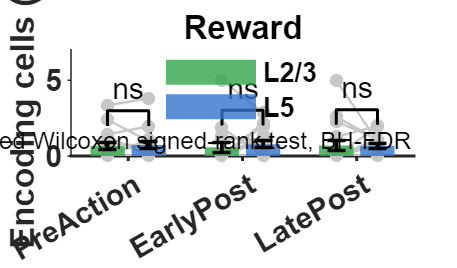

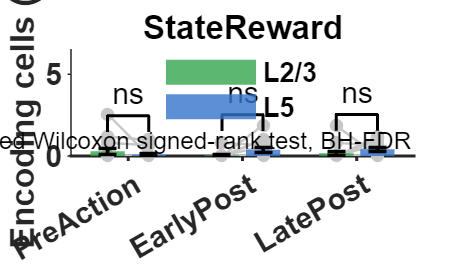

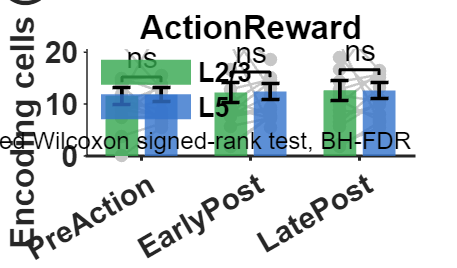

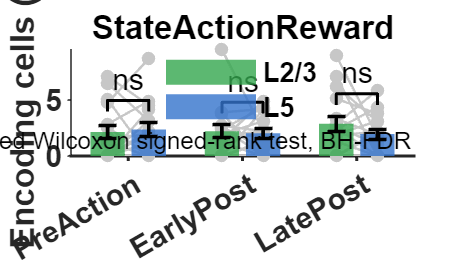



%% ========================================================================
% Save
% ========================================================================

save( ...
    fullfile( ...
    output_dir, ...
    'task_variable_encoding_GLM_by_layer.mat'), ...
    'task_glm_results', ...
    'task_glm_layer_summary', ...
    'task_glm_layer_comparison', ...
    'layer_group_comparison', ...
    'glm_windows', ...
    'glm_cell_p_threshold', ...
    '-v7.3');

writetable( ...
    task_glm_layer_summary, ...
    fullfile( ...
    output_dir, ...
    'task_variable_encoding_GLM_by_layer.csv'));

writetable( ...
    layer_group_comparison, ...
    fullfile( ...
    output_dir, ...
    'task_variable_encoding_L23_vs_L5.csv'));


%% ========================================================================
% Plot: L2/3 vs L5 with significance
%
% Bar plot        = mean ± SEM
% Individual data = light gray paired lines
%
% L2/3 = green
% L5   = blue
%
% Statistical significance:
%   Primary = BH-FDR corrected QValue
%
% Significance labels:
%   ns     q >= 0.05
%   *      q < 0.05
%   **     q < 0.01
%   ***    q < 0.001
%
% ========================================================================


%% ------------------------------------------------------------------------
% Plot parameters
% -------------------------------------------------------------------------

color_L23 = [0.20 0.65 0.30];      % green
color_L5  = [0.20 0.45 0.80];      % blue

color_session = [0.78 0.78 0.78]; % light gray

bar_width = 0.30;
x_offset  = 0.18;

% true  -> use BH-FDR corrected q-value
% false -> use raw p-value
use_FDR_for_plot = true;

% Show "ns"
show_ns = true;


%% ========================================================================
% Plot loop
% ========================================================================

for i_effect = 1:n_effects

    figure( ...
        'Position',[100 100 850 500]);

    hold on;


    %% --------------------------------------------------------------------
    % Prepare data containers
    % ---------------------------------------------------------------------

    mean_L23 = nan(1,n_glm_windows);
    mean_L5  = nan(1,n_glm_windows);

    sem_L23 = nan(1,n_glm_windows);
    sem_L5  = nan(1,n_glm_windows);

    p_plot = nan(1,n_glm_windows);


    %% --------------------------------------------------------------------
    % Plot individual sessions first
    % ---------------------------------------------------------------------

    for i_window = 1:n_glm_windows

        window_name = ...
            string(glm_windows(i_window).name);

        effect_name = ...
            string(effect_names{i_effect});


        % -------------------------------------------------------------
        % Session-level proportions
        % -------------------------------------------------------------

        idx = ...
            task_glm_layer_comparison.Window == window_name & ...
            task_glm_layer_comparison.Effect == effect_name;

        p23 = ...
            task_glm_layer_comparison.Prop_L23(idx) * 100;

        p5 = ...
            task_glm_layer_comparison.Prop_L5(idx) * 100;

        valid_pair = ...
            isfinite(p23) & ...
            isfinite(p5);

        p23 = p23(valid_pair);
        p5  = p5(valid_pair);


        % -------------------------------------------------------------
        % X positions
        % -------------------------------------------------------------

        x23 = ...
            i_window - x_offset;

        x5 = ...
            i_window + x_offset;


        % -------------------------------------------------------------
        % Individual session paired lines
        % -------------------------------------------------------------

        for ii = 1:length(p23)

            plot( ...
                [x23 x5], ...
                [p23(ii) p5(ii)], ...
                '-', ...
                'Color', color_session, ...
                'LineWidth',0.8, ...
                'HandleVisibility','off');

            scatter( ...
                x23, ...
                p23(ii), ...
                20, ...
                color_session, ...
                'filled', ...
                'HandleVisibility','off');

            scatter( ...
                x5, ...
                p5(ii), ...
                20, ...
                color_session, ...
                'filled', ...
                'HandleVisibility','off');

        end


        %% -------------------------------------------------------------
        % Mean
        % -------------------------------------------------------------

        mean_L23(i_window) = ...
            mean(p23,'omitnan');

        mean_L5(i_window) = ...
            mean(p5,'omitnan');


        %% -------------------------------------------------------------
        % SEM
        % -------------------------------------------------------------

        n23 = nnz(isfinite(p23));
        n5  = nnz(isfinite(p5));

        if n23 > 1

            sem_L23(i_window) = ...
                std(p23,'omitnan') / sqrt(n23);

        elseif n23 == 1

            sem_L23(i_window) = 0;

        end

        if n5 > 1

            sem_L5(i_window) = ...
                std(p5,'omitnan') / sqrt(n5);

        elseif n5 == 1

            sem_L5(i_window) = 0;

        end


        %% -------------------------------------------------------------
        % Statistical value for plotting
        %
        % Across-session paired comparison:
        % Wilcoxon signed-rank test
        % -------------------------------------------------------------

        idx_stat = ...
            layer_group_comparison.Window == window_name & ...
            layer_group_comparison.Effect == effect_name;

        if nnz(idx_stat) == 1

            if use_FDR_for_plot

                p_plot(i_window) = ...
                    layer_group_comparison.QValue(idx_stat);

            else

                p_plot(i_window) = ...
                    layer_group_comparison.PValue(idx_stat);

            end

        end

    end


    %% --------------------------------------------------------------------
    % Bars
    % ---------------------------------------------------------------------

    x_base = 1:n_glm_windows;

    x23_all = ...
        x_base - x_offset;

    x5_all = ...
        x_base + x_offset;


    b23 = bar( ...
        x23_all, ...
        mean_L23, ...
        bar_width, ...
        'FaceColor',color_L23, ...
        'EdgeColor','none', ...
        'FaceAlpha',0.80);


    b5 = bar( ...
        x5_all, ...
        mean_L5, ...
        bar_width, ...
        'FaceColor',color_L5, ...
        'EdgeColor','none', ...
        'FaceAlpha',0.80);


    %% --------------------------------------------------------------------
    % Error bars
    % ---------------------------------------------------------------------

    errorbar( ...
        x23_all, ...
        mean_L23, ...
        sem_L23, ...
        'k', ...
        'LineStyle','none', ...
        'LineWidth',1.2, ...
        'CapSize',6, ...
        'HandleVisibility','off');


    errorbar( ...
        x5_all, ...
        mean_L5, ...
        sem_L5, ...
        'k', ...
        'LineStyle','none', ...
        'LineWidth',1.2, ...
        'CapSize',6, ...
        'HandleVisibility','off');


    %% ====================================================================
    % Significance bars
    % =====================================================================

    % Current maximum data value
    all_values = [ ...
        mean_L23 + sem_L23, ...
        mean_L5 + sem_L5];

    current_max = ...
        max(all_values,[],'omitnan');

    if isempty(current_max) || ...
       ~isfinite(current_max)

        current_max = 1;

    end

    % Height settings
    sig_offset = max(2, current_max * 0.08);
    sig_height = max(1, current_max * 0.03);

    sig_y_all = nan(1,n_glm_windows);


    for i_window = 1:n_glm_windows

        p_current = ...
            p_plot(i_window);

        if ~isfinite(p_current)
            continue;
        end


        %% -------------------------------------------------------------
        % Convert p/q value into significance label
        % -------------------------------------------------------------

        if p_current < 0.001

            sig_label = '***';

        elseif p_current < 0.01

            sig_label = '**';

        elseif p_current < 0.05

            sig_label = '*';

        else

            sig_label = 'ns';

        end


        if strcmp(sig_label,'ns') && ~show_ns
            continue;
        end


        %% -------------------------------------------------------------
        % Position of significance bar
        % -------------------------------------------------------------

        local_max = max( ...
            [ ...
            mean_L23(i_window) + sem_L23(i_window), ...
            mean_L5(i_window)  + sem_L5(i_window) ...
            ], ...
            [], ...
            'omitnan');

        if ~isfinite(local_max)

            local_max = 0;

        end

        y_sig = ...
            local_max + sig_offset;

        sig_y_all(i_window) = ...
            y_sig;


        %% -------------------------------------------------------------
        % Horizontal significance line
        % -------------------------------------------------------------

        x1 = ...
            x23_all(i_window);

        x2 = ...
            x5_all(i_window);


        plot( ...
            [x1 x1 x2 x2], ...
            [ ...
            y_sig-sig_height, ...
            y_sig, ...
            y_sig, ...
            y_sig-sig_height ...
            ], ...
            'k-', ...
            'LineWidth',1.0, ...
            'HandleVisibility','off');


        %% -------------------------------------------------------------
        % Significance text
        % -------------------------------------------------------------

        text( ...
            mean([x1 x2]), ...
            y_sig + 0.3*sig_height, ...
            sig_label, ...
            'HorizontalAlignment','center', ...
            'VerticalAlignment','bottom', ...
            'FontSize',10, ...
            'HandleVisibility','off');

    end


    %% --------------------------------------------------------------------
    % Axis limits
    % ---------------------------------------------------------------------

    max_sig_y = ...
        max(sig_y_all,[],'omitnan');

    if isfinite(max_sig_y)

        y_upper = ...
            max_sig_y + 2*sig_offset;

    else

        y_upper = ...
            current_max + 2*sig_offset;

    end

    ylim([0 y_upper]);


    %% --------------------------------------------------------------------
    % Axis labels
    % ---------------------------------------------------------------------

    xticks(1:n_glm_windows);

    xticklabels( ...
        {glm_windows.name});

    xlim([0.5 n_glm_windows+0.5]);

    ylabel('Encoding cells (%)');


    %% --------------------------------------------------------------------
    % Title
    % ---------------------------------------------------------------------

    title_text = ...
        strrep(effect_names{i_effect}, ...
        '_',' ');

    title(title_text);


    %% --------------------------------------------------------------------
    % Legend
    % ---------------------------------------------------------------------

    legend( ...
        [b23 b5], ...
        {'L2/3','L5'}, ...
        'Location','best', ...
        'Box','off');


    %% --------------------------------------------------------------------
    % Appearance
    % ---------------------------------------------------------------------

    box off;

    set(gca, ...
        'TickDir','out', ...
        'LineWidth',1, ...
        'FontSize',10);


    %% --------------------------------------------------------------------
    % Optional statistical-method annotation
    % ---------------------------------------------------------------------

    if use_FDR_for_plot

        annotation_text = ...
            'paired Wilcoxon signed-rank test, BH-FDR';

    else

        annotation_text = ...
            'paired Wilcoxon signed-rank test';

    end

    text( ...
        0.99, ...
        0.02, ...
        annotation_text, ...
        'Units','normalized', ...
        'HorizontalAlignment','right', ...
        'VerticalAlignment','bottom', ...
        'FontSize',8);


    %% --------------------------------------------------------------------
    % Save
    % ---------------------------------------------------------------------

    filename_base = ...
        sprintf( ...
        'L23_vs_L5_%s', ...
        effect_names{i_effect});

    saveas( ...
        gcf, ...
        fullfile( ...
        output_dir, ...
        [filename_base '.png']));

    % Vector format for figures
    exportgraphics( ...
        gcf, ...
        fullfile( ...
        output_dir, ...
        [filename_base '.pdf']), ...
        'ContentType','vector');

end

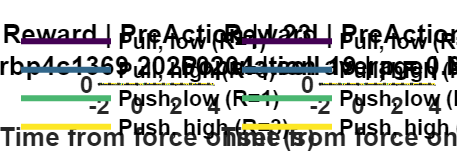

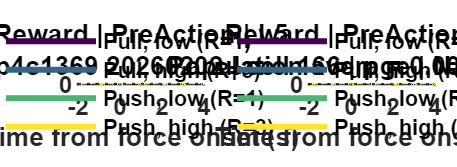

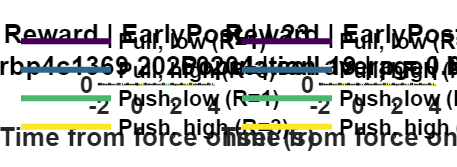

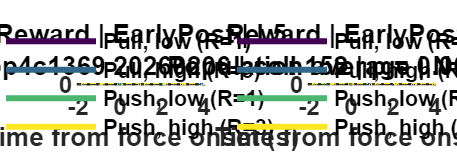

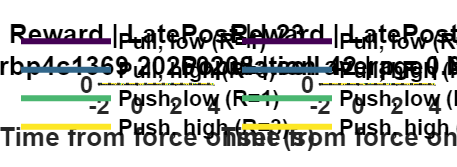

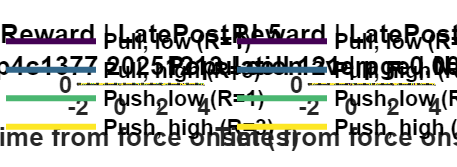

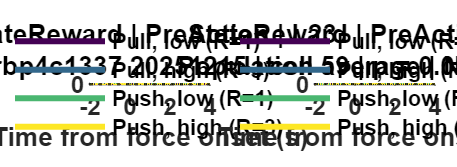

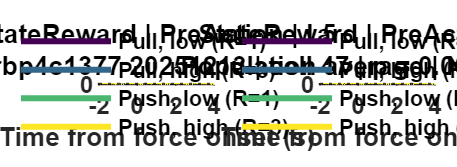

%% ========================================================================
% ETA plots for encoding cells
%
% Representative cell:
%   For each effect x window x layer, choose the encoding cell with
%   the smallest p-value.
%
% Population average:
%   For each effect x window x layer, compute ETA for all encoding cells.
%   First average across trials within each cell, then average across cells.
%
% Conditions:
%   1. Pull, low reward
%   2. Pull, high reward
%   3. Push, low reward
%   4. Push, high reward
%
% Alignment:
%   force onset = 0 s
%
% ETA window:
%   -2 to +4 s
%
% Normalization:
%   Cell-wise z-score using all eligible trials in baseline [-2, 0) s
%
% ========================================================================


%% ------------------------------------------------------------------------
% Parameters
% -------------------------------------------------------------------------

eta_start_s = -2;
eta_end_s   =  4;

eta_frames = ...
    round(eta_start_s * fps) : round(eta_end_s * fps);

eta_time = eta_frames / fps;

% Baseline for cell-wise normalization
baseline_start_s = -2;
baseline_end_s   =  0;

baseline_frames = ...
    round(baseline_start_s * fps) : ...
    round(baseline_end_s * fps) - 1;

% Viridis colors
eta_colors = viridis_local(4);

% Effects/windows to plot
plot_effect_idx = 1:n_effects;
plot_window_idx = 1:n_glm_windows;

effect_pval_names = { ...
    'RewardZ', ...
    'StateReward', ...
    'ActionReward', ...
    'StateActionReward'};

eta_layer_names  = {'L23', 'L5'};
eta_layer_values = [1, 0];


%% ------------------------------------------------------------------------
% Build Action x Reward event table for each session
% -------------------------------------------------------------------------

eta_event_tables = cell(length(Animal),1);

for i_animal = 1:length(Animal)

    trial = trial_sessions{i_animal};

    pullResistance = pullResistance_sessions{i_animal};
    pushResistance = pushResistance_sessions{i_animal};
    pushReward      = pushReward_sessions{i_animal};

    pull_event_idx = force_idx_sessions{i_animal}(:);
    push_event_idx = force_idx2_sessions{i_animal}(:);

    eta_event_tables{i_animal} = ...
        build_action_reward_event_table( ...
            trial, ...
            pullResistance, ...
            pushResistance, ...
            pushReward, ...
            pull_event_idx, ...
            push_event_idx, ...
            fps, ...
            glm_reward_high_thr, ...
            glm_reward_low_thr, ...
            glm_reward_sum);

end


%% ========================================================================
% Plot loop
% ========================================================================

for i_effect = plot_effect_idx

    effect_name = string(effect_names{i_effect});
    pval_name   = string(effect_pval_names{i_effect});

    for i_window = plot_window_idx

        window_name = string(glm_windows(i_window).name);

        for i_layer = 1:2

            layer_name  = string(eta_layer_names{i_layer});
            layer_value = eta_layer_values(i_layer);


            %% ------------------------------------------------------------
            % Representative cell + population storage
            % -------------------------------------------------------------

            best_p = inf;
            rep_session = NaN;
            rep_cell    = NaN;

            % Each element:
            % rows = encoding cells
            % cols = ETA time points
            pooled_cell_eta = cell(4,1);


            %% ============================================================
            % Session loop
            % ============================================================

            for i_animal = 1:length(Animal)

                result_now = ...
                    task_glm_results{i_animal, i_window};

                if isempty(result_now)
                    continue;
                end

                event_tbl = ...
                    eta_event_tables{i_animal};

                if isempty(event_tbl) || height(event_tbl) == 0
                    continue;
                end


                %% --------------------------------------------------------
                % Candidate encoding cells
                % ---------------------------------------------------------

                cell_layer = ...
                    result_now.cell_layer(:);

                enc_mask = ...
                    result_now.encoding_cells.(effect_name);

                p_vec = ...
                    result_now.p_values.(pval_name);

                candidate_cells = find( ...
                    cell_layer == layer_value & ...
                    enc_mask & ...
                    isfinite(p_vec));

                if isempty(candidate_cells)
                    continue;
                end


                %% --------------------------------------------------------
                % Representative cell
                % ---------------------------------------------------------

                [p_min_session, loc_min] = ...
                    min(p_vec(candidate_cells));

                if p_min_session < best_p

                    best_p = p_min_session;
                    rep_session = i_animal;
                    rep_cell = candidate_cells(loc_min);

                end


                %% --------------------------------------------------------
                % Session data
                % ---------------------------------------------------------

                neural_data = ...
                    acc_neural_activity_data_all_sessions{i_animal};

                n_frames = ...
                    size(neural_data,1);

                reward_levels = ...
                    sort(unique(event_tbl.RewardAmount));

                if length(reward_levels) ~= 2
                    continue;
                end

                reward_low  = reward_levels(1);
                reward_high = reward_levels(2);


                %% --------------------------------------------------------
                % Four Action x Reward conditions
                % ---------------------------------------------------------

                condition_masks = { ...
                    event_tbl.ActionCode == -0.5 & ...
                    event_tbl.RewardAmount == reward_low, ...
                    ...
                    event_tbl.ActionCode == -0.5 & ...
                    event_tbl.RewardAmount == reward_high, ...
                    ...
                    event_tbl.ActionCode ==  0.5 & ...
                    event_tbl.RewardAmount == reward_low, ...
                    ...
                    event_tbl.ActionCode ==  0.5 & ...
                    event_tbl.RewardAmount == reward_high};


                %% --------------------------------------------------------
                % All eligible events for baseline normalization
                %
                % IMPORTANT:
                % baseline mean/SD are calculated using ALL retained events
                % across the four conditions.
                % ---------------------------------------------------------

                all_events = ...
                    event_tbl.EventIndex;

                valid_baseline_event = ...
                    all_events + min(baseline_frames) >= 1 & ...
                    all_events + max(baseline_frames) <= n_frames;

                all_events_for_baseline = ...
                    all_events(valid_baseline_event);


                %% --------------------------------------------------------
                % Condition event indices valid for full ETA window
                % ---------------------------------------------------------

                condition_events = cell(4,1);

                for i_cond = 1:4

                    ev = ...
                        event_tbl.EventIndex(condition_masks{i_cond});

                    valid_ev = ...
                        ev + min(eta_frames) >= 1 & ...
                        ev + max(eta_frames) <= n_frames;

                    condition_events{i_cond} = ...
                        ev(valid_ev);

                end


                %% ========================================================
                % Process each encoding cell
                % ========================================================

                for ii_cell = 1:length(candidate_cells)

                    c = candidate_cells(ii_cell);


                    %% ----------------------------------------------------
                    % Cell-wise baseline statistics
                    %
                    % Pool baseline samples from ALL eligible trials.
                    % -----------------------------------------------------

                    baseline_samples = [];

                    for i_ev = 1:length(all_events_for_baseline)

                        idx = ...
                            all_events_for_baseline(i_ev) + ...
                            baseline_frames;

                        baseline_samples = [ ...
                            baseline_samples; ...
                            neural_data(idx,c)];

                    end

                    baseline_mean = ...
                        mean(baseline_samples, 'omitnan');

                    baseline_std = ...
                        std(baseline_samples, 0, 'omitnan');


                    % Skip cells that cannot be normalized
                    if ~isfinite(baseline_mean) || ...
                       ~isfinite(baseline_std) || ...
                       baseline_std <= 0
                        continue;
                    end


                    %% ----------------------------------------------------
                    % ETA for four conditions
                    % -----------------------------------------------------

                    temp_cell_eta = ...
                        nan(4, length(eta_time));

                    for i_cond = 1:4

                        ev = ...
                            condition_events{i_cond};

                        if isempty(ev)
                            continue;
                        end

                        temp_trials = ...
                            nan(length(ev), length(eta_time));


                        for i_ev = 1:length(ev)

                            idx = ...
                                ev(i_ev) + eta_frames;

                            raw_trace = ...
                                neural_data(idx,c);

                            % Cell-wise z-score
                            temp_trials(i_ev,:) = ...
                                (raw_trace - baseline_mean) ./ ...
                                baseline_std;

                        end


                        % Trial average for this cell
                        temp_cell_eta(i_cond,:) = ...
                            mean(temp_trials,1,'omitnan');

                    end


                    %% ----------------------------------------------------
                    % Only include cells represented in all 4 conditions
                    % -----------------------------------------------------

                    if all(any(isfinite(temp_cell_eta),2))

                        for i_cond = 1:4

                            pooled_cell_eta{i_cond}(end+1,:) = ...
                                temp_cell_eta(i_cond,:);

                        end

                    end

                end

            end


            %% ------------------------------------------------------------
            % Skip if no representative encoding cell
            % -------------------------------------------------------------

            if ~isfinite(rep_session) || ...
               ~isfinite(rep_cell)
                continue;
            end


            %% ============================================================
            % Representative cell ETA
            % ============================================================

            rep_neural_data = ...
                acc_neural_activity_data_all_sessions{rep_session};

            rep_event_tbl = ...
                eta_event_tables{rep_session};

            rep_n_frames = ...
                size(rep_neural_data,1);

            rep_reward_levels = ...
                sort(unique(rep_event_tbl.RewardAmount));

            if length(rep_reward_levels) ~= 2
                continue;
            end

            reward_low  = rep_reward_levels(1);
            reward_high = rep_reward_levels(2);


            cond_labels = { ...
                sprintf('Pull, low (R=%g)', reward_low), ...
                sprintf('Pull, high (R=%g)', reward_high), ...
                sprintf('Push, low (R=%g)', reward_low), ...
                sprintf('Push, high (R=%g)', reward_high)};


            rep_condition_masks = { ...
                rep_event_tbl.ActionCode == -0.5 & ...
                rep_event_tbl.RewardAmount == reward_low, ...
                ...
                rep_event_tbl.ActionCode == -0.5 & ...
                rep_event_tbl.RewardAmount == reward_high, ...
                ...
                rep_event_tbl.ActionCode ==  0.5 & ...
                rep_event_tbl.RewardAmount == reward_low, ...
                ...
                rep_event_tbl.ActionCode ==  0.5 & ...
                rep_event_tbl.RewardAmount == reward_high};


            %% ------------------------------------------------------------
            % Baseline statistics for representative cell
            % -------------------------------------------------------------

            rep_all_events = ...
                rep_event_tbl.EventIndex;

            rep_valid_baseline_event = ...
                rep_all_events + min(baseline_frames) >= 1 & ...
                rep_all_events + max(baseline_frames) <= rep_n_frames;

            rep_baseline_events = ...
                rep_all_events(rep_valid_baseline_event);

            rep_baseline_samples = [];

            for i_ev = 1:length(rep_baseline_events)

                idx = ...
                    rep_baseline_events(i_ev) + ...
                    baseline_frames;

                rep_baseline_samples = [ ...
                    rep_baseline_samples; ...
                    rep_neural_data(idx, rep_cell)];

            end

            rep_baseline_mean = ...
                mean(rep_baseline_samples,'omitnan');

            rep_baseline_std = ...
                std(rep_baseline_samples,0,'omitnan');

            if ~isfinite(rep_baseline_std) || ...
               rep_baseline_std <= 0
                continue;
            end


            %% ------------------------------------------------------------
            % Representative ETA
            % -------------------------------------------------------------

            rep_mean = ...
                nan(4,length(eta_time));

            rep_sem = ...
                nan(4,length(eta_time));

            rep_n_trials = ...
                zeros(4,1);


            for i_cond = 1:4

                ev = ...
                    rep_event_tbl.EventIndex( ...
                    rep_condition_masks{i_cond});

                valid_ev = ...
                    ev + min(eta_frames) >= 1 & ...
                    ev + max(eta_frames) <= rep_n_frames;

                ev = ev(valid_ev);

                rep_n_trials(i_cond) = ...
                    length(ev);

                if isempty(ev)
                    continue;
                end

                temp_trials = ...
                    nan(length(ev),length(eta_time));

                for i_ev = 1:length(ev)

                    idx = ...
                        ev(i_ev) + eta_frames;

                    raw_trace = ...
                        rep_neural_data(idx,rep_cell);

                    temp_trials(i_ev,:) = ...
                        (raw_trace - rep_baseline_mean) ./ ...
                        rep_baseline_std;

                end

                rep_mean(i_cond,:) = ...
                    mean(temp_trials,1,'omitnan');

                rep_sem(i_cond,:) = ...
                    std(temp_trials,0,1,'omitnan') ./ ...
                    sqrt(sum(isfinite(temp_trials),1));

            end


            %% ============================================================
            % Population average
            % ============================================================

            pop_mean = ...
                nan(4,length(eta_time));

            pop_sem = ...
                nan(4,length(eta_time));

            pop_n_cells = ...
                zeros(4,1);


            for i_cond = 1:4

                X = ...
                    pooled_cell_eta{i_cond};

                if isempty(X)
                    continue;
                end

                pop_n_cells(i_cond) = ...
                    size(X,1);

                pop_mean(i_cond,:) = ...
                    mean(X,1,'omitnan');

                pop_sem(i_cond,:) = ...
                    std(X,0,1,'omitnan') ./ ...
                    sqrt(sum(isfinite(X),1));

            end

            total_pop_cells = ...
                size(pooled_cell_eta{1},1);


            %% ====================================================================
            % Plot
            % =====================================================================

            figure( ...
                'Position',[100 100 1150 420]);

            tiledlayout(1,2, ...
                'Padding','compact', ...
                'TileSpacing','compact');


            %% ------------------------------------------------------------
            % Representative cell
            % -------------------------------------------------------------

            nexttile;
            hold on;

            for i_cond = 1:4

                if all(~isfinite(rep_mean(i_cond,:)))
                    continue;
                end

                plot_eta_mean_sem( ...
                    eta_time, ...
                    rep_mean(i_cond,:), ...
                    rep_sem(i_cond,:), ...
                    eta_colors(i_cond,:));

            end

            xline(0,'k--','LineWidth',1);
            yline(0,'k:','LineWidth',0.8);

            xlabel('Time from force onset (s)');
            ylabel('Z-scored activity');

            xlim([eta_start_s eta_end_s]);

            title({ ...
                sprintf('%s | %s | %s', ...
                    effect_name, ...
                    window_name, ...
                    layer_name), ...
                sprintf( ...
                    'Representative: %s %s | cell %d | p = %.3g', ...
                    string(Animal{rep_session}), ...
                    string(Date{rep_session}), ...
                    rep_cell, ...
                    best_p)});

            legend( ...
                cond_labels, ...
                'Location','best', ...
                'Box','off');

            box off;

            set(gca, ...
                'TickDir','out', ...
                'LineWidth',1);


            %% ------------------------------------------------------------
            % Population average
            % -------------------------------------------------------------

            nexttile;
            hold on;

            for i_cond = 1:4

                if all(~isfinite(pop_mean(i_cond,:)))
                    continue;
                end

                plot_eta_mean_sem( ...
                    eta_time, ...
                    pop_mean(i_cond,:), ...
                    pop_sem(i_cond,:), ...
                    eta_colors(i_cond,:));

            end

            xline(0,'k--','LineWidth',1);
            yline(0,'k:','LineWidth',0.8);

            xlabel('Time from force onset (s)');
            ylabel('Z-scored activity');

            xlim([eta_start_s eta_end_s]);

            title({ ...
                sprintf('%s | %s | %s', ...
                    effect_name, ...
                    window_name, ...
                    layer_name), ...
                sprintf( ...
                    'Population average | N = %d cells', ...
                    total_pop_cells)});

            legend( ...
                cond_labels, ...
                'Location','best', ...
                'Box','off');

            box off;

            set(gca, ...
                'TickDir','out', ...
                'LineWidth',1);


            %% ------------------------------------------------------------
            % Save
            % -------------------------------------------------------------

            filename_base = ...
                sprintf( ...
                    'ETA_zscore_%s_%s_%s', ...
                    effect_name, ...
                    window_name, ...
                    layer_name);

            saveas( ...
                gcf, ...
                fullfile( ...
                    output_dir, ...
                    [filename_base '.png']));

            exportgraphics( ...
                gcf, ...
                fullfile( ...
                    output_dir, ...
                    [filename_base '.pdf']), ...
                'ContentType','vector');

        end

    end

end

% Code for plot of prediction error and action value (simple way)

no_reward_idx_sessions     = cell(1,length(Animal));
push_trial_push_prob_block_idx_sessions = cell(1,length(Animal));
push_trial_pull_prob_block_idx_sessions = cell(1,length(Animal));
pull_trial_push_prob_block_idx_sessions = cell(1,length(Animal));
pull_trial_pull_prob_block_idx_sessions = cell(1,length(Animal));
push_trial_push_value_block_idx_sessions = cell(1,length(Animal));
push_trial_pull_value_block_idx_sessions = cell(1,length(Animal));
pull_trial_push_value_block_idx_sessions = cell(1,length(Animal));
pull_trial_pull_value_block_idx_sessions = cell(1,length(Animal));
push_trial_push_prob_block_idx2_sessions = cell(1,length(Animal));
push_trial_pull_prob_block_idx2_sessions = cell(1,length(Animal));
pull_trial_push_prob_block_idx2_sessions = cell(1,length(Animal));
pull_trial_pull_prob_block_idx2_sessions = cell(1,length(Animal));
push_trial_push_value_block_idx2_sessions = cell(1,length(Animal));
push_trial_pull_value_block_idx2_sessions = cell(1,length(Animal));
pull_trial_push_value_block_idx2_sessions = cell(1,length(Animal));
pull_trial_pull_value_block_idx2_sessions = cell(1,length(Animal));

for i_animal = 1:length(Animal)
    % % split trials and eta anlysis for detecting prediction error or action
    % % value
    trial        = trial_sessions{i_animal};
    pullResistance = pullResistance_sessions{i_animal};
    pushResistance = pushResistance_sessions{i_animal};
    pushCorrect = pushCorrect_sessions{i_animal};
    pushReward = pushReward_sessions{i_animal};

    no_reward_idx = [];
    reward_idx = reward_idx_sessions{i_animal};
    force_idx = force_idx_sessions{i_animal};
    force_idx2 = force_idx2_sessions{i_animal};     
    trial_start_idx = trial_start_idx_sessions{i_animal};
    trial_end_idx = trial_end_idx_sessions{i_animal};
    for i = 1:length(trial_end_idx)
        if any(reward_idx >= i & reward_idx < i+fps)% there is reward_idx == j
            continue;% skip for loop
        end
        no_reward_idx(end+1) = trial_end_idx(i); % no reward within 1 seconds
    %     if trial_end_idx(i) reward_idx % no reward within 1 seconds
    %         no_reward_idx(end+1) = trial_end_idx(i)
    %     end
    end
    % force during trial in which session type == trial type
    % force during trial in which session type != trial type (sensory prediction error)
    push_trial_push_prob_block_idx = [];
    push_trial_pull_prob_block_idx = [];
    pull_trial_push_prob_block_idx = [];
    pull_trial_pull_prob_block_idx = [];
    push_trial_push_value_block_idx = [];
    push_trial_pull_value_block_idx = [];
    pull_trial_push_value_block_idx = [];
    pull_trial_pull_value_block_idx = [];
    for i = 1:length(force_idx)
        if force_idx(i)+fps < length(trial)
            temp_trial = max(trial(force_idx(i):force_idx(i)+fps));% expand 1 sec to include force just before trial
            if temp_trial > 0
                temp_pull_resistance = pullResistance(temp_trial); 
                if pullResistance(temp_trial) > pushResistance(temp_trial)
                    if pushCorrect(temp_trial) > 0.51
                        push_trial_push_prob_block_idx(end+1) = force_idx(i);
                    elseif  pushCorrect(temp_trial) < 0.49
                        push_trial_pull_prob_block_idx(end+1) = force_idx(i);
                    end
                    if pushReward(temp_trial) > 2.1
                        push_trial_push_value_block_idx(end+1) = force_idx(i);
                    elseif  pushReward(temp_trial) < 1.9
                        push_trial_pull_value_block_idx(end+1) = force_idx(i);
                    end
                elseif pullResistance(temp_trial) < pushResistance(temp_trial)
                    if pushCorrect(temp_trial) > 0.51
                        pull_trial_push_prob_block_idx(end+1) = force_idx(i);
                    elseif  pushCorrect(temp_trial) < 0.49
                        pull_trial_pull_prob_block_idx(end+1) = force_idx(i);
                    end
                    if pushReward(temp_trial) > 2.1
                        pull_trial_push_value_block_idx(end+1) = force_idx(i);
                    elseif  pushReward(temp_trial) < 1.9
                        pull_trial_pull_value_block_idx(end+1) = force_idx(i);
                    end 
                end
            end
        end
    end
    push_trial_push_prob_block_idx2 = [];
    push_trial_pull_prob_block_idx2 = [];
    pull_trial_push_prob_block_idx2 = [];
    pull_trial_pull_prob_block_idx2 = [];
    push_trial_push_value_block_idx2 = [];
    push_trial_pull_value_block_idx2 = [];
    pull_trial_push_value_block_idx2 = [];
    pull_trial_pull_value_block_idx2 = [];    
    for i = 1:length(force_idx2)
        if force_idx2(i)+fps < length(trial)
            temp_trial = max(trial(force_idx2(i):force_idx2(i)+fps));% expand 1 sec to include force just before trial
            if temp_trial > 0
                temp_pull_resistance = pullResistance(temp_trial); 
                if pullResistance(temp_trial) > pushResistance(temp_trial)
                    if pushCorrect(temp_trial) > 0.51
                        push_trial_push_prob_block_idx2(end+1) = force_idx2(i);
                    elseif  pushCorrect(temp_trial) < 0.49
                        push_trial_pull_prob_block_idx2(end+1) = force_idx2(i);
                    end
                    if pushReward(temp_trial) > 2.1
                        push_trial_push_value_block_idx2(end+1) = force_idx2(i);
                    elseif  pushReward(temp_trial) < 1.9
                        push_trial_pull_value_block_idx2(end+1) = force_idx2(i);
                    end
                elseif pullResistance(temp_trial) < pushResistance(temp_trial)
                    if pushCorrect(temp_trial) > 0.51
                        pull_trial_push_prob_block_idx2(end+1) = force_idx2(i);
                    elseif  pushCorrect(temp_trial) < 0.49
                        pull_trial_pull_prob_block_idx2(end+1) = force_idx2(i);
                    end
                    if pushReward(temp_trial) > 2.1
                        pull_trial_push_value_block_idx2(end+1) = force_idx2(i);
                    elseif  pushReward(temp_trial) < 1.9
                        pull_trial_pull_value_block_idx2(end+1) = force_idx2(i);
                    end 
                end
            end
        end
    end

    no_reward_idx_sessions{i_animal}     = no_reward_idx;
    push_trial_push_prob_block_idx_sessions{i_animal} = push_trial_push_prob_block_idx;
    push_trial_pull_prob_block_idx_sessions{i_animal} = push_trial_pull_prob_block_idx;
    pull_trial_push_prob_block_idx_sessions{i_animal} = pull_trial_push_prob_block_idx;
    pull_trial_pull_prob_block_idx_sessions{i_animal} = pull_trial_pull_prob_block_idx;
    push_trial_push_value_block_idx_sessions{i_animal} = push_trial_push_value_block_idx;
    push_trial_pull_value_block_idx_sessions{i_animal} = push_trial_pull_value_block_idx;
    pull_trial_push_value_block_idx_sessions{i_animal} = pull_trial_push_value_block_idx;
    pull_trial_pull_value_block_idx_sessions{i_animal} = pull_trial_pull_value_block_idx;
    push_trial_push_prob_block_idx2_sessions{i_animal} = push_trial_push_prob_block_idx2;
    push_trial_pull_prob_block_idx2_sessions{i_animal} = push_trial_pull_prob_block_idx2;
    pull_trial_push_prob_block_idx2_sessions{i_animal} = pull_trial_push_prob_block_idx2;
    pull_trial_pull_prob_block_idx2_sessions{i_animal} = pull_trial_pull_prob_block_idx2;
    push_trial_push_value_block_idx2_sessions{i_animal} = push_trial_push_value_block_idx2;
    push_trial_pull_value_block_idx2_sessions{i_animal} = push_trial_pull_value_block_idx2;
    pull_trial_push_value_block_idx2_sessions{i_animal} = pull_trial_push_value_block_idx2;
    pull_trial_pull_value_block_idx2_sessions{i_animal} = pull_trial_pull_value_block_idx2;
end    

eta_acts_sessions = cell(1,length(Animal));
max_acts_sessions = cell(1,length(Animal));
% max_I_sessions = cell(1,length(Animal));
% max_act_times_sessions = cell(1,length(Animal));
sig_cell_idxs2_sessions = cell(1,length(Animal));
eta_acts_train_raw_sessions = cell(1,length(Animal));
eta_acts_train_test_sessions = cell(1,length(Animal));

for i_animal = 1:length(Animal)
    eta_acts = cell(1,18);
    eta_actss = cell(1,18);
    eta_acts_train = cell(1,18);
    eta_acts_test = cell(1,18);
    eta_idxs = {reward_idx_sessions{i_animal}, no_reward_idx_sessions{i_animal}, push_trial_push_prob_block_idx_sessions{i_animal}, push_trial_pull_prob_block_idx_sessions{i_animal}, pull_trial_push_prob_block_idx_sessions{i_animal}, pull_trial_pull_prob_block_idx_sessions{i_animal}, ...
        push_trial_push_value_block_idx_sessions{i_animal}, push_trial_pull_value_block_idx_sessions{i_animal}, pull_trial_push_value_block_idx_sessions{i_animal}, pull_trial_pull_value_block_idx_sessions{i_animal},...
        push_trial_push_prob_block_idx2_sessions{i_animal}, push_trial_pull_prob_block_idx2_sessions{i_animal}, pull_trial_push_prob_block_idx2_sessions{i_animal}, pull_trial_pull_prob_block_idx2_sessions{i_animal},...
        push_trial_push_value_block_idx2_sessions{i_animal}, push_trial_pull_value_block_idx2_sessions{i_animal}, pull_trial_push_value_block_idx2_sessions{i_animal}, pull_trial_pull_value_block_idx2_sessions{i_animal}}; %{reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_value_idx, action_no_value_idx};
    % eta_idxs = {reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_no_value_idx, action_value_idx}; %{reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_value_idx, action_no_value_idx};
    % eta_idx_idxs = [2,1,4,3,5,6];
    max_acts = cell(1,18);
    sig_cell_idxs2 = cell(1,18);
    % max_I = cell(1,6);
    % max_act_times = cell(1,6);    
    for i = 1:length(eta_acts)
        eta_acts{i} = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
        exception_count = 0;
        i_eta_acts = {};
        for j = 1:length(eta_idxs{i})
            if eta_idxs{i}(j)-fps*before_event<=0 | eta_idxs{i}(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
                exception_count = exception_count + 1;
            else
                eta_acts{i} = eta_acts{i}+transpose(acc_neural_activity_data_all_sessions{i_animal}(eta_idxs{i}(j)-fps*before_event:eta_idxs{i}(j)+fps*after_event,:));
                i_eta_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(eta_idxs{i}(j)-fps*before_event:eta_idxs{i}(j)+fps*after_event,:));
            end
        end
        eta_acts{i} = eta_acts{i}/(length(eta_idxs{i})-exception_count);
        i_eta_acts = reshape(cell2mat(i_eta_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(eta_acts{i},2) length(eta_idxs{i})-exception_count]); %-1]);
        eta_actss{i} = i_eta_acts;
        if norm == 1
            eta_acts{i} = normalize_rows(eta_acts{i});
        elseif norm ==2
            eta_acts{i} = zscore_rows(eta_acts{i}); 
        elseif norm ==6
           eta_acts{i} = zscore_rows_by_before_pull(eta_acts{i});            
        elseif norm ==3
            sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
            for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
                [~,max_idx] = max(mean(i_eta_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
                max_acts{i} = reshape(i_eta_acts(i_cell,max_idx,:), [], 1);
                [h,p] = ttest2(squeeze(i_eta_acts(i_cell,:)),squeeze(max_acts{i}),'Vartype','unequal'); %temporal,'Alpha',0.001
    %             [h,p] = ttest2(squeeze(i_eta_acts(i_cell,:)),squeeze(max_acts{i}),'Vartype','unequal','Alpha',0.001); %temporal,'Alpha',0.001
                if h == 1
                    sig_cell_idx(i_cell) = 1;
                else
                    sig_cell_idx(i_cell) = 0;
                end
                sig_cell_idxs2{i} = sig_cell_idx;
            end
            eta_acts{i} = zscore_rows(eta_acts{i}(find(sig_cell_idx==1),:));
        elseif norm == 4 % zscored no error activity by error or action value activity
            if i == 2 || i == 4 || i == 6
                eta_acts{i} = zscore_rows_by_diff_matrix(eta_acts{i},eta_old);
            else
                eta_old = eta_acts{i};
                eta_acts{i} = zscore_rows(eta_acts{i}); 
            end
        elseif norm == 5
            % separete train and test of trial_start_acts
            L = size(i_eta_acts, 3);
            % 最後の次元に基づいてランダムにインデックスをシャッフル
            indices = randperm(L);        
            % インデックスを2つのグループに分ける
            half_L1 = ceil(L / 2); % (L+1)/2のサイズ
            half_L2 = floor(L / 2); % (L-1)/2のサイズ        
            indices1 = indices(1:half_L1);
            indices2 = indices(half_L1+1:end);
            % 2つのテンソルに分割
            i_eta_acts_train = i_eta_acts(:, :, indices1);
            i_eta_acts_test  = i_eta_acts(:, :, indices2);
            % sort with train data
            i_eta_act_train_raw = mean(i_eta_acts_train,3);
            i_eta_act_test_raw  = mean(i_eta_acts_test,3);
            eta_acts_train{i} = i_eta_act_train_raw;
            eta_acts_test{i} = i_eta_act_test_raw;
        end
    end
    eta_acts_sessions{i_animal} = eta_acts;
    max_acts_sessions{i_animal} = max_acts;
    sig_cell_idxs2_sessions{i_animal} = sig_cell_idxs2;
    eta_acts_train_raw_sessions{i_animal} = eta_acts_train;
    eta_acts_test_raw_sessions{i_animal} = eta_acts_test;    
end

max_I = cell(1,18);
max_act_times = cell(1,18);
eta_acts_conc = eta_acts_sessions{1};
eta_acts_max_act_times_conc = max_acts_sessions{1};
eta_acts_train_raw_conc = eta_acts_train_raw_sessions{1};
eta_acts_test_raw_conc = eta_acts_test_raw_sessions{1};
sig_cell_idxs2_conc = sig_cell_idxs2_sessions{1};
sortedAreas_conc = cell(1,18);

for i = 1:length(eta_acts)    
    for i_animal = 2:length(Animal)
        eta_acts_conc{i} = vertcat(eta_acts_conc{i}, eta_acts_sessions{i_animal}{i});
        eta_acts_max_act_times_conc{i} = vertcat(eta_acts_max_act_times_conc{i}, max_acts_sessions{i_animal}{i});
        sig_cell_idxs2_conc{i} = horzcat(sig_cell_idxs2_conc{i}, sig_cell_idxs2_sessions{i_animal}{i});
        eta_acts_train_raw_conc{i} = vertcat(eta_acts_train_raw_conc{i}, eta_acts_train_raw_sessions{i_animal}{i});
        eta_acts_test_raw_conc{i} = vertcat(eta_acts_test_raw_conc{i}, eta_acts_test_raw_sessions{i_animal}{i});
    end
    [M,max_I{i}] = max(eta_acts_conc{i},[],2);

    if norm==3
        eta_acts_conc{i} = cat(2, max_I{i},pointAreas_conc(find(sig_cell_idxs2_conc{i} == 1)) ,eta_acts_conc{i});
    else
        % eta_acts_conc{i} = cat(2, max_I{i}, eta_acts_conc{i});             
        eta_acts_conc{i} = cat(2, max_I{i},pointAreas_conc ,eta_acts_conc{i});        
    end
    eta_acts_conc{i} = sortrows(eta_acts_conc{i});
    max_act_times{i} = eta_acts_conc{i}(:,1)/10 -2;
    sortedAreas_conc{i} = eta_acts_conc{i}(:,2);
    eta_acts_conc{i}(:,1:2) = [];    
    % eta_acts_conc{i}(:,1) = [];
    if norm == 5
        trial_len = size(eta_acts_train_raw_conc{i},2);
        [M,max_I{i}] = max(eta_acts_train_raw_conc{i},[],2);
        eta_acts_conc{i} = cat(2,max_I{i},eta_acts_train_raw_conc{i}, eta_acts_test_raw_conc{i});
        eta_acts_conc{i} = sortrows(eta_acts_conc{i});
        max_act_times{i} = eta_acts_conc{i}(:,1)/10 -2;
        eta_acts_conc{i}(:,1) = [];
        % trial_start_act_train = eta_acts{i}(:,1:trial_len);
        i_eta_act_test  = eta_acts_conc{i}(:,trial_len+1:size(eta_acts_conc{i},2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        eta_acts_conc{i} = zscore_rows(i_eta_act_test);
    end    
end

% write eta code by categrizing neurons by layers

if strcmp(categorize, 'layer') == 1
    % align concatenated eta neural activities
    [M,trial_start_i] = max(trial_start_act_conc,[],2);
    [M,trial_end_i] = max(trial_end_act_conc,[],2);  
    [M,position_i] = max(position_act_conc,[],2);
    [M,force_i] = max(force_act_conc,[],2);
    [M,force_i2] = max(force_act2_conc,[],2);    
    [M,reward_i] = max(reward_act_conc,[],2);

    if norm==3
        trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc(find(sig_cell_idxs_conc{1} == 1)) ,trial_start_act_conc);
        trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc(find(sig_cell_idxs_conc{2} == 1)) ,trial_end_act_conc);
        position_act_conc = cat(2, position_i,pointAreas_conc(find(sig_cell_idxs_conc{3} == 1)) ,position_act_conc);
        force_act_conc = cat(2, force_i,pointAreas_conc(find(sig_cell_idxs_conc{4} == 1)) ,force_act_conc);
        force_act2_conc = cat(2, force_i2,pointAreas_conc(find(sig_cell_idxs_conc{6} == 1)) ,force_act2_conc);
        reward_act_conc = cat(2, reward_i,pointAreas_conc(find(sig_cell_idxs_conc{5} == 1)) ,reward_act_conc);
    else
        trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc ,trial_start_act_conc);
        trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc ,trial_end_act_conc);
        position_act_conc = cat(2, position_i,pointAreas_conc ,position_act_conc);
        force_act_conc = cat(2, force_i,pointAreas_conc ,force_act_conc);
        force_act2_conc = cat(2, force_i2,pointAreas_conc ,force_act2_conc);       
        reward_act_conc = cat(2, reward_i,pointAreas_conc ,reward_act_conc);
    end

    trial_start_act_conc =   sortrows(trial_start_act_conc);
    trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startAreas = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];

    trial_end_act_conc =   sortrows(trial_end_act_conc);
    trial_end_act_max_act_time_conc = trial_end_act_conc(:,1)/10 -2;
    endAreas = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];  

    position_act_conc =   sortrows(position_act_conc);
    position_act_max_act_time_conc = position_act_conc(:,1)/10 -2;
    positionAreas = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];    

    force_act_conc =   sortrows(force_act_conc);
    force_act_max_act_time_conc = force_act_conc(:,1)/10 -2;
    forceAreas = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];    

    force_act2_conc =   sortrows(force_act2_conc);
    force_act2_max_act_time_conc = force_act2_conc(:,1)/10 -2;
    forceAreas2 = force_act2_conc(:,2);
    force_act2_conc(:,1:2) = [];    

    reward_act_conc =   sortrows(reward_act_conc);
    reward_act_max_act_time_conc = reward_act_conc(:,1)/10 -2;
    rewardAreas = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];    

    % specify layer specific activity
    trial_start_act_layer23_conc = trial_start_act_conc(find(startAreas == 1),:);
    trial_start_act_layer5_conc  = trial_start_act_conc(find(startAreas == 0),:);
    trial_end_act_layer23_conc = trial_end_act_conc(find(endAreas == 1),:);
    trial_end_act_layer5_conc  = trial_end_act_conc(find(endAreas == 0),:);
    position_act_layer23_conc = position_act_conc(find(positionAreas == 1),:);
    position_act_layer5_conc  = position_act_conc(find(positionAreas == 0),:);
    force_act_layer23_conc = force_act_conc(find(forceAreas == 1),:);
    force_act_layer5_conc  = force_act_conc(find(forceAreas == 0),:);
    force_act2_layer23_conc = force_act2_conc(find(forceAreas2 == 1),:);
    force_act2_layer5_conc  = force_act2_conc(find(forceAreas2 == 0),:);    
    reward_act_layer23_conc = reward_act_conc(find(rewardAreas == 1),:);
    reward_act_layer5_conc  = reward_act_conc(find(rewardAreas == 0),:);
end

% eta_layer23_acts_sessions = cell(1,length(Animal));
% eta_layer5_acts_sessions  = cell(1,length(Animal));
% etaAreas_sessions         = cell(1,length(Animal));
% pointAreas_cell2_sessions = cell(1,length(Animal));
% 
% for i_animal = 1:length(Animal)
%     eta_layer23_acts = cell(1,6);
%     eta_layer5_acts  = cell(1,6);
%     etaAreas         = cell(1,6);
%     pointAreas_cell2 = cell(1,6);
% 
%     if categorize == 'layer' 
%         if norm==3
%             for i = 1:length(eta_acts)
%                 pointAreas_cell2{i} = pointAreas{i_animal}(find(sig_cell_idxs2_sessions{i_animal}{i} == 1));          
%                 etaAreas{i} = cat(2,max_I_sessions{i_animal}{i},pointAreas_cell2{i});
%                 etaAreas{i} = sortrows(etaAreas{i});
%                 etaAreas{i}(:,1) = [];
%                 eta_layer23_acts{i} = eta_acts_sessions{i_animal}{i}(find(etaAreas{i} == 1),:);
%                 eta_layer5_acts{i}  = eta_acts_sessions{i_animal}{i}(find(etaAreas{i} == 0),:);
%             end
%         else
%             for i = 1:length(eta_acts)
%                 etaAreas{i} = cat(2,max_I_sessions{i_animal}{i},pointAreas{i_animal});
%                 etaAreas{i} = sortrows(etaAreas{i});
%                 etaAreas{i}(:,1) = [];
%                 eta_layer23_acts{i} = eta_acts_sessions{i_animal}{i}(find(etaAreas{i} == 1),:);
%                 eta_layer5_acts{i}  = eta_acts_sessions{i_animal}{i}(find(etaAreas{i} == 0),:);
%             end
%         end
%     end
%     eta_layer23_acts_sessions{i_animal} = eta_layer23_acts;
%     eta_layer5_acts_sessions{i_animal}  = eta_layer5_acts;
%     etaAreas_sessions{i_animal}         = etaAreas;
%     pointAreas_cell2_sessions{i_animal} = pointAreas_cell2;    
% end

% eta_acts_conc = eta_acts_sessions{1};
% eta_layer23_acts_conc = eta_layer23_acts_sessions{1};
% eta_layer5_acts_conc = eta_layer5_acts_sessions{1};
% for i_animal = 2:length(Animal)
%     for i = 1:length(eta_acts_sessions{i_animal})
%         eta_acts_conc{i} = vertcat(eta_acts_conc{i}, eta_acts_sessions{i_animal}{i});
%         eta_layer23_acts_conc{i} = vertcat(eta_layer23_acts_conc{i}, eta_layer23_acts_sessions{i_animal}{i});
%         eta_layer5_acts_conc{i} = vertcat(eta_layer5_acts_conc{i}, eta_layer5_acts_sessions{i_animal}{i});        
%     end
% end

image_raw =     0.9758    0.7921    0.9324    0.8636    0.7041    0.7570    0.7135    0.7138    0.7333    0.6465    0.7519    0.6467    0.5984    0.6366    0.6189    0.6754    0.6016    0.5725    0.5329    0.3073    0.0975   -0.3112   -0.5576   -1.0470   -1.4942   -2.0531   -2.5010   -2.6210   -2.6361   -2.5413   -2.1566   -1.5358   -1.1492   -0.7185   -0.6783   -0.2783   -0.2045   -0.0765   -0.0234    0.0024    0.0423    0.0195    0.0022   -0.0546    0.0729    0.0326   -0.0209    0.0899    0.2402    0.3569
    1.0128    1.0001    0.9666    0.9653    0.9340    0.9822    0.9376    0.9134    0.9103    0.8632    0.7800    0.7948    0.7383    0.6300    0.5973    0.4800    0.4002    0.4961    0.4879    0.5417    0.6854    0.6811    0.5853    0.2660   -0.0399   -0.2930   -0.6143   -0.8960   -1.1612   -1.2994   -1.4565   -1.4894   -1.5812   -1.5953   -1.6736   -1.7406   -1.7675   -1.7670   -1.7707   -1.7278   -1.5535   -1.3038   -1.0328   -0.8926   -0.6439   -0.4974   -0.2864   -0.0188    0.2

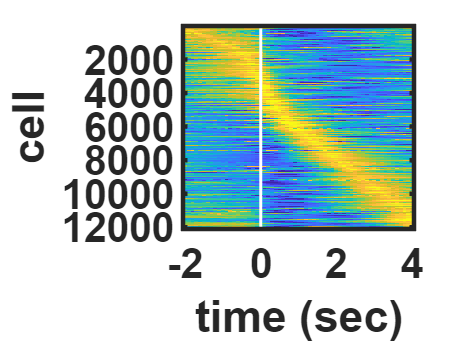

image_raw =     0.8387    0.7772    0.7363    0.5707    0.5856    0.3689    0.3428    0.4740    0.6184    0.5361    0.7952    0.6855    0.7701    0.7021    0.6206    0.4968    0.5472    0.8035    0.7317    0.5654    0.6320    0.3444   -0.2998   -1.0716   -1.4891   -1.8925   -2.2828   -2.4600   -2.3883   -2.2781   -2.2883   -1.9130   -1.6163   -1.5509   -1.3118   -0.6683   -0.5940   -0.0572    0.0493    0.2136    0.3336    0.3914    0.5837    0.7236    0.6765    0.7489    0.6958    0.6302    0.4875    0.4689
    1.0143    0.8233    0.8944    0.8475    0.8548    0.8175    0.6744    0.9674    0.7138    0.6351    0.8556    0.8876    0.6367    0.7735    0.5951    0.6115    0.7571    0.6560    0.7796    0.4418    0.3267    0.2922   -0.2143   -0.7927   -1.2862   -1.6965   -1.7921   -1.9322   -1.7798   -1.9330   -1.6484   -1.7722   -1.6007   -1.6087   -1.4877   -1.4882   -1.3713   -1.2288   -1.0412   -1.0722   -0.5353   -0.3508   -0.1211    0.3663    0.3472    0.5960    0.7065    0.6754    0.8

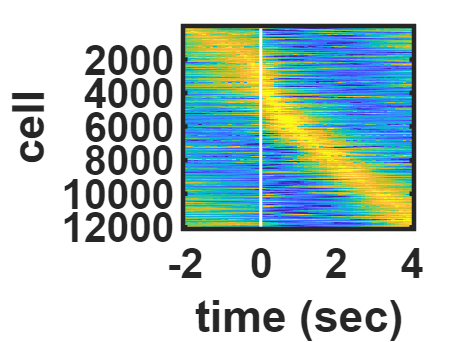

image_raw =     1.1901    1.1365    1.1530    1.0597    0.7897    0.8220    0.7190    0.5632    0.5595    0.5851    0.6066    0.5247    0.6466    0.5943    0.4450    0.2138    0.2835   -0.0160   -0.1527   -0.6083   -1.4230   -1.5186   -1.4371   -2.0572   -2.3519   -2.2564   -2.0690   -1.6766   -1.5613   -1.5092   -1.3526   -1.2910   -1.3468   -0.9821   -0.6911   -0.3102   -0.2609   -0.1364   -0.0372    0.1244    0.1378    0.1726    0.2144    0.1290    0.2105    0.2420    0.6273    0.7493    0.6363    0.8712
    1.2563    1.0504    0.9743    0.8516    0.8169    0.7230    0.7612    0.6596    0.7414    0.7848    0.5967    0.7807    0.8063    1.1009    1.0571    1.1963    1.2367    0.9681    0.9306    1.0509    1.1379    1.2429    1.1828    1.0281    0.9224    0.9778    0.8717    0.6787    0.5199    0.3047    0.1177    0.2118    0.0501   -0.0369    0.0568   -0.2853   -0.2346   -0.4151   -0.4805   -0.7304   -0.8872   -0.9858   -1.2026   -1.2518   -1.2536   -1.3070   -1.4248   -1.4374   -1.5

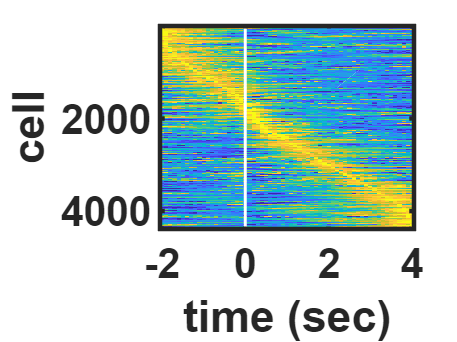

image_raw =     1.2538    1.1393    1.0717    1.1479    1.0244    1.0771    1.0714    1.2017    0.9116    1.1151    1.2529    1.0070    0.9260    0.7638    0.9243    0.6993    0.7658    0.8651    0.6169    0.6489    0.4447    0.2159   -0.0819    0.0144    0.0470    0.2315    0.2972    0.5399    0.4064    0.5433    0.5328    0.7768    0.5732    0.4030    0.4982    0.4212    0.0994   -0.0029   -0.1106   -0.2396   -0.3668   -0.3676   -0.4249   -0.3681   -0.5290   -0.7278   -0.8122   -0.9234   -1.0473   -1.0146
    1.3433    1.2655    1.2170    0.9764    1.0690    0.9499    0.9753    0.8804    0.9582    0.9632    1.0506    1.2194    0.6926    0.6961    0.7763    0.6409    0.4861    0.5900    0.7376    0.7062    0.7663    0.8114    0.4553    0.4816    0.8295    0.5280    0.5243    0.4022    0.3451    0.2728    0.2803    0.2389    0.1038    0.1460    0.1884   -0.0028    0.2138    0.1637    0.0347    0.2207   -0.0097   -0.0835   -0.2612   -0.4610   -0.5796   -0.6543   -0.9376   -1.0780   -1.0

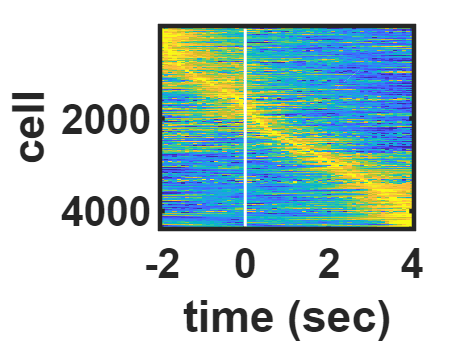

image_raw =     1.3046    0.4920    0.9423    1.2067    0.7641    0.9782    0.6152    0.6015    0.5644    0.2784    0.9502    0.9546    0.8049    1.0042    0.9168    0.3847    0.7514    0.7638    0.9449    0.4503    0.3870    0.1536   -0.5458   -0.8982   -1.5113   -1.9703   -2.5484   -2.6743   -2.0619   -2.2972   -2.1637   -1.5289   -1.6164   -0.8810   -0.3641    0.2225    0.2644    0.3540    0.6430    0.7629    0.5119    0.2783    0.1271    0.4511    0.6050    1.0020    0.7312    0.5092    0.5111    0.1037
    1.4394    1.4260    1.2682    1.3325    1.2756    1.1122    1.3430    1.0620    1.0457    1.1275    1.1549    1.1190    1.0343    0.8435    0.8112    0.8204    0.9868    0.9143    1.0242    1.0687    1.2345    1.1237    0.7638    0.5929    0.7269    0.3365    0.2633    0.0601    0.4478    0.0183    0.0250   -0.0568   -0.1288   -0.1685   -0.3818   -0.5833   -0.4463   -0.6230   -0.6936   -0.8978   -0.8468   -0.9946   -0.9894   -0.8843   -1.0739   -0.9643   -1.1144   -1.1182   -1.0

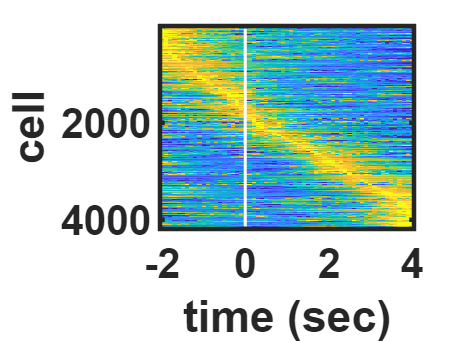

image_raw =     0.8153    0.6464    0.7600    0.6273    0.4460    0.4640    0.3246    0.3254    0.3339    0.5618    0.4470    0.4288    0.3203    0.2937    0.1739    0.2924    0.2786    0.1881    0.5757    0.6737    0.3410   -0.6853   -1.3697   -2.4252   -3.1410   -2.6385   -2.4416   -2.3947   -1.9991   -1.6268   -1.5566   -1.1008   -0.5563   -0.1697   -0.2216   -0.1683    0.1137    0.2535    0.3859    0.2548    0.3832    0.2465    0.3249    0.6426    0.5653    0.4404    0.7111    0.6964    0.6077    0.6104
    1.3258    1.2963    1.3122    1.0725    1.2310    1.1327    1.2425    1.2120    1.0518    1.0866    1.1320    1.1031    1.0767    0.9742    1.0943    1.1394    1.0369    1.1793    0.9996    0.8649    0.8793    0.6385    0.5814    0.5097    0.5299    0.4309    0.3346    0.3419    0.1972    0.0525    0.0551    0.0696    0.0574   -0.1061   -0.2364   -0.2880   -0.2985   -0.5789   -0.4331   -0.6603   -0.7847   -1.0080   -0.8611   -1.1755   -1.2378   -1.2574   -1.3575   -1.3973   -1.4

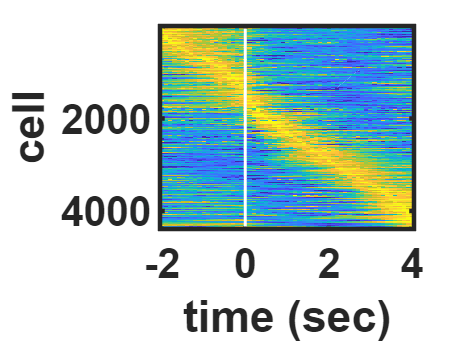

image_raw =     1.2843    1.1907    1.2477    0.9156    0.9660    1.0114    0.9077    1.0622    0.9272    0.7525    0.5805    0.9341    0.8007    0.5072    0.3073    0.6798    0.8027    0.6154    0.6725    0.9026    0.8122    0.9543    1.0507    0.8141    0.7149    0.7062    0.4069    0.2576    0.4073    0.2895    0.2789    0.0663    0.2751    0.0052    0.3367    0.3495    0.3083    0.2639    0.4032    0.1345    0.0569   -0.3769   -0.3159   -0.7852   -0.6127   -0.9025   -1.0256   -0.8711   -1.2651   -1.4097
    1.3117    0.9653    0.7441    1.0087    0.3916    0.6049    0.6555    0.8691    0.4240    0.3801   -0.1682    0.1911    0.3164    0.2971   -0.2417    0.2164   -0.3247   -0.1759   -0.2510   -0.7727   -0.8984   -1.4281   -2.4472   -2.2370   -2.6221   -2.5096   -2.2157   -1.7550   -1.6660   -1.0546   -0.5542   -0.4982   -0.3799    0.0245    0.7394    0.3589    0.6818    0.8279    0.9466    1.0307    1.2534    0.9610    1.0184    0.8903    0.8146    0.8956    0.8501    0.2541    0.9

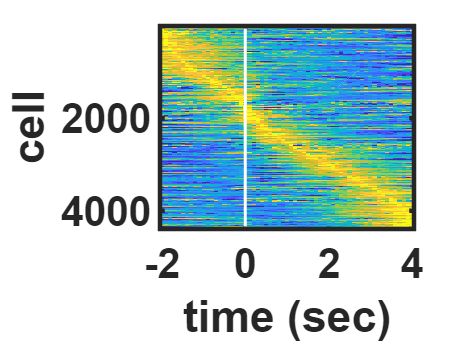

image_raw =     1.3703    1.3525    1.0163    0.9949    0.8229    0.7700    1.1229    0.5700    0.8463    1.0076    0.9500    0.9125    0.6574    0.7734   -0.1548    0.3844    0.4324    0.7139    0.3620   -0.4189    0.1882    0.6564    1.0661    0.7112    0.2244   -0.2800   -0.0316    0.2137   -0.0203    0.2584    0.5748    0.3533    0.2149    0.2662    0.0215   -0.2804    0.0913    0.4104    0.6994    0.5902    0.3813    0.4227    0.1683    0.3851    0.0986   -0.2357    0.0432   -0.6691   -1.1953   -0.2614
    1.3861    1.2783    1.2604    1.1785    1.1076    1.1486    1.0549    1.0422    1.0423    1.0112    1.0018    0.9414    0.8991    0.8487    0.7611    0.6514    0.6569    0.4932    0.5103    0.4775    0.4199    0.3974    0.3045    0.1167   -0.0129   -0.3812   -0.7110   -0.8481   -0.7806   -0.8705   -0.7723   -0.5447   -0.2768   -0.0354    0.0961    0.2759    0.2644    0.4027    0.7015    0.5498    0.4874    0.4659    0.4698    0.3469    0.1303    0.1213    0.0704   -0.0658   -0.2

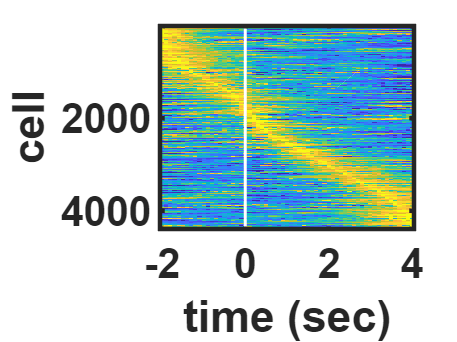

image_raw =     1.2461    1.2375    1.1883    1.1094    1.1035    0.9919    1.0048    1.0064    0.9008    0.9389    0.8834    1.0215    0.9855    1.0161    0.9818    0.8743    0.8164    0.7891    0.8371    0.8822    0.9357    0.9102    0.8642    0.8541    0.7436    0.6209    0.5894    0.7003    0.4301    0.3408    0.1761    0.1164    0.1413    0.0118   -0.0471   -0.1592   -0.2152   -0.3408   -0.4193   -0.4669   -0.5549   -0.7148   -0.6639   -0.7801   -0.8859   -0.9422   -0.8729   -0.9875   -1.1554   -1.1463
    1.2547    1.1706    1.0728    1.0352    1.0213    0.9747    0.8589    0.7178    0.6276    0.5729    0.5995    0.4211    0.3555    0.3050    0.2162    0.2261    0.1826    0.2178    0.2130    0.2900    0.2010    0.1283    0.2538    0.2506    0.3417    0.2757    0.3239    0.3977    0.4729    0.6733    0.8074    0.8318    0.8911    1.0296    1.0424    0.9997    0.8763    0.7523    0.6488    0.4733    0.2909    0.1814    0.0487   -0.2162   -0.2158   -0.4470   -0.6977   -0.7937   -0.9

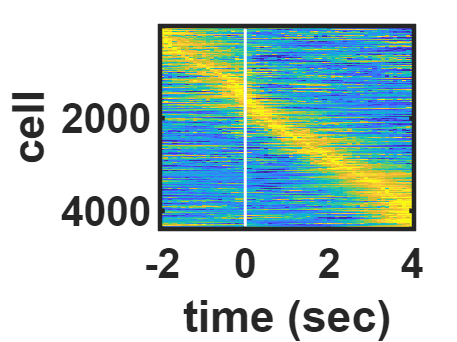

image_raw =     1.3398    1.1037    1.0419    1.0730    0.8805    0.7772    0.7495    0.7205    0.7426    0.7547    0.7929    0.8410    1.0183    0.9788    0.9987    0.9311    0.7357    0.8309    0.9119    0.7716    0.9141    0.7329    0.5857    0.9929    0.7276    0.7820    0.8466    0.6303    0.6227    0.5351    0.5466    0.5538    0.2230    0.3603    0.2477    0.0191   -0.1132   -0.1098   -0.3713   -0.4146   -0.4806   -0.5766   -0.6795   -0.6847   -0.8520   -1.1274   -1.0748   -1.0572   -1.1466   -1.2620
    1.3870    1.2854    1.2855    1.1935    1.1681    1.3057    1.2980    1.1039    1.1269    0.8747    0.9537    0.8666    0.6793    0.6923    0.9417    1.2308    1.2038    1.2621    1.3772    1.3597    1.2821    1.2527    0.8835    0.6665    0.4399    0.4663    0.1817    0.1298   -0.0800   -0.2010   -0.2559   -0.0072   -0.2542   -0.2783   -0.5137   -0.4540   -0.7886   -0.7343   -1.0016   -1.2032   -1.1769   -1.2273   -1.1062   -1.1532   -1.0606   -0.9747   -1.0873   -0.8918   -1.1

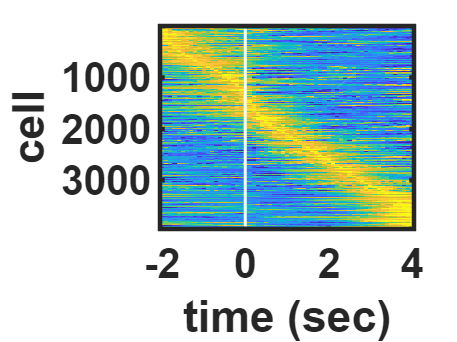

image_raw =     1.1462    1.0636    1.1154    0.8640    1.1402    1.1243    0.5165    0.5819    0.6063    0.3525    0.2341    0.1994    0.2316    0.4390    0.5413    0.6475    0.6213    0.4877    0.5313    0.3941    0.2385   -0.2604    0.2145    0.5524    0.5144    0.9144    0.8833    0.8803    1.0170    0.9536    1.0421    0.9122    0.7985    0.7144    0.5226    0.4931    0.3708    0.4172    0.3330    0.1570    0.1066   -0.0223   -0.1478   -0.3442   -0.4569   -0.5274   -0.7219   -0.8453   -0.8557   -0.9692
    1.1891    1.1574    1.1638    0.6904    0.5260    0.6681    0.5561    0.8866    0.6185    0.8968    0.7228    0.7562    0.9041    0.6499    0.5688    0.6532    0.1876    0.1500    0.4482    0.3924    0.4764    0.9720    0.8954    1.0109    0.8957    0.7653    0.4734    0.6699    0.7497    0.8849    0.8267    0.5933    0.5121    0.5682    0.4712    0.3994    0.3878    0.0917    0.0276   -0.1830    0.0649   -0.1079   -0.1635   -0.2343   -0.4850   -0.5654   -0.8491   -0.9627   -1.2

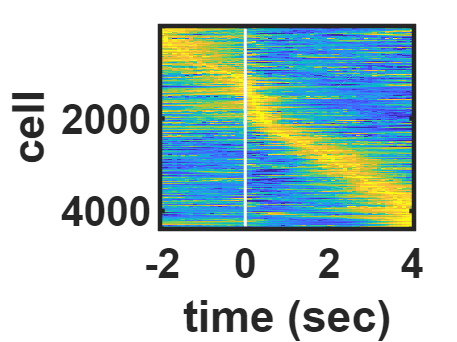

image_raw =     1.2357    1.1639    1.1951    0.8069    0.8877    0.9006    0.7867    0.3333    0.7938    0.8178    0.6273    0.3668    0.7186    0.6244    0.6164    0.6163    0.5946    0.6488    0.8315    0.6383    0.5984    0.7061    1.2285    0.9685    0.2738    0.5003    0.6142    0.6937    0.0361    0.2998    0.5206    0.2013    0.2673    0.2410    0.1771    0.5472    0.4541    0.5401    0.3511    0.1013   -0.2489   -0.0795   -0.2995   -0.1965   -0.1133   -0.3558   -0.5468   -0.8015   -0.7796   -1.0699
    1.3382    1.1995    1.0536    0.7306    0.9422    0.7473    1.1279    1.0100    1.0779    1.2879    0.9025    0.6844    0.9034    0.5422    0.9137    0.8630    0.7648    0.7248    1.2750    0.8009    0.7882    0.4564    0.8277    0.5380    0.7057    0.9073    0.5303    0.7354    0.4004    0.3936    0.4581    0.4163    0.4034    0.1904    0.3484    0.2431   -0.0392   -0.1418   -0.3119   -0.6358   -0.5401   -0.3966   -0.3778   -0.9185   -0.9436   -1.2003   -1.1727   -1.3055   -1.4

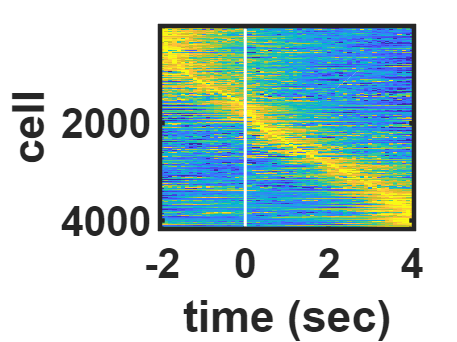

image_raw =     1.4147    0.9050    0.5801    0.7237    0.7930    0.9733    0.7262    0.5254    1.3100    0.3181    0.4734    1.0417    0.8648    1.2716    1.1335    0.8843    0.7299    0.2212    0.7789    0.9647    0.9849    1.2585    1.3551    1.2180    1.2795    0.2130    0.4542    0.1807    0.4789    0.0521   -0.1471   -0.2582   -0.1929   -0.4304    0.0410   -0.2564    0.0839    0.0534    0.0968    0.1690    0.2957   -0.3043   -0.2246   -0.2078    0.0739   -1.1202   -1.0548   -0.7045   -1.1160   -0.7020
    1.4643    1.1783    0.9998    0.8565    0.9095    0.9408    0.8463    0.8564    0.8310    1.0833    0.4605    0.7693    0.9259    1.3328    1.4309    0.8810    1.3512    1.0546    1.0085    0.5969    0.9961    0.9999    0.8069    0.7348    0.5465    0.5128    0.3138    0.3071    0.3086    0.1512   -0.3161    0.1037   -0.0634   -0.1460    0.0608    0.1992    0.4156   -0.0758   -0.0062   -0.1484    0.0519   -0.4194   -0.6342   -0.7883   -0.9044   -1.1645   -1.5339   -1.4917   -1.5

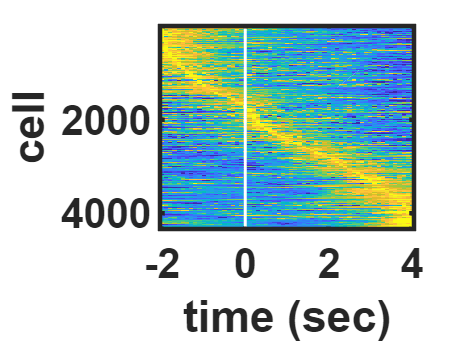

image_raw =     1.3381    1.2950    1.1750    1.1075    1.1288    0.9712    0.9898    1.0922    0.7140    0.7349    0.8825    1.0875    0.9498    1.0331    1.0528    1.3079    0.6823    1.1477    1.1024    1.1242    0.7418    0.8861    0.8290    0.9409    0.7751    0.4217    0.4932    0.2486    0.4335    0.2467    0.4126    0.1321   -0.0102   -0.0589   -0.1149   -0.3465   -0.3153   -0.3533   -0.4278   -0.4961   -0.5726   -0.7495   -0.8424   -0.7794   -1.0903   -1.1648   -1.0774   -1.1525   -1.0960   -1.2706
    1.3519    1.2255    1.3510    1.1934    1.1003    0.9885    0.8661    0.7391    0.5102    0.4815    0.3485    0.2085    0.2415    0.1245    0.0346   -0.1858   -0.2191   -0.2937   -0.3473   -0.4606   -0.5572   -0.8410   -0.7998   -1.0226   -1.1920   -1.3655   -1.5709   -1.7284   -1.7707   -1.7523   -1.7317   -1.6461   -1.7749   -1.5931   -1.4708   -1.2608   -1.0083   -0.7793   -0.5871   -0.2660   -0.1404    0.0056    0.1805    0.3254    0.5460    0.6444    0.7160    0.8187    0.8

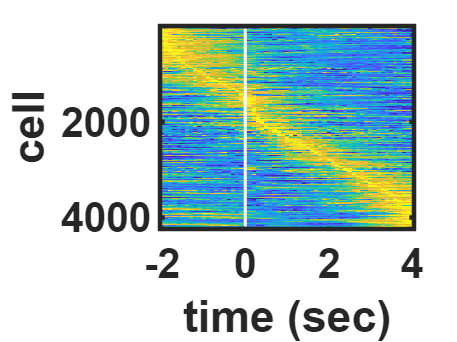

image_raw =     1.2793    1.1935    0.8632    0.8569    0.7454    0.5459    0.7809    1.2075    1.0529    0.9707    0.7522    0.6550    0.5751    0.4680    0.3874    0.3465    0.6109    0.5480    0.7153    0.4703    0.4080    0.6775    0.7688    0.5874    0.2872   -0.0951   -0.2841   -0.5782   -0.6479   -0.9913   -1.1897   -1.4167   -1.4572   -1.6534   -1.7828   -1.9480   -1.8377   -1.7937   -1.6879   -1.4715   -1.4625   -1.4305   -1.3596   -1.1291   -0.9507   -0.8519   -0.5286   -0.3613    0.1834    0.2527
    1.3428    0.6319    0.5988    0.9770    0.3037    1.3204    0.8619    0.6355    0.1804    0.7096   -0.8531    0.0520    0.2050    0.2128   -0.3932   -1.9595    0.0114   -0.5990   -0.8914   -1.3141   -1.3464    0.1575    0.7015    0.5821   -0.2457   -2.1714   -1.5761   -1.7981   -2.1329   -2.3251   -1.2527   -1.2601   -0.6435   -0.9400   -1.7997   -1.1561    0.0721    0.0793    0.3868    0.5819    0.5072    0.1259    0.9307    1.2063    1.2005    0.8323    0.3551    0.7405    0.4

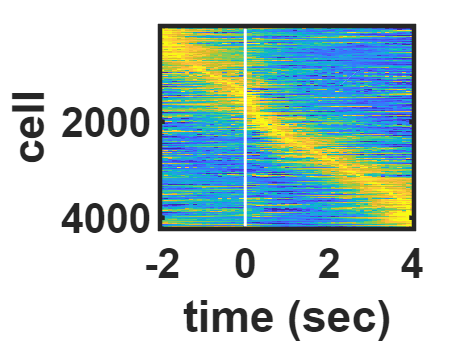

image_raw =     1.3482    1.0895    0.9222    0.9211    0.7072    0.9954    0.7598    0.7617    0.9001    1.0807    0.7609    0.9326    0.9742    1.2683    1.1746    1.2000    1.0570    1.1769    1.2064    1.2017    1.2020    1.0348    1.0836    0.4982    0.3411    0.0247   -0.0805    0.0654   -0.0692   -0.1894   -0.2346   -0.2243   -0.3783   -0.1566    0.0455   -0.2383    0.0852   -0.2020   -0.0407   -0.0026   -0.0635    0.2180   -0.0254   -0.2720   -0.6521   -0.7060   -0.7061   -0.9454   -1.0782   -1.2241
    1.3757    1.3306    0.3314   -0.4671    0.4239    0.6439   -0.0842    0.6601    1.0473   -0.3317    1.2494    1.0981    0.9129    0.8253    0.9369    1.3238    0.9049    0.7062    0.4088    0.6969    0.9416    0.0219    0.8186    1.0854    0.0467    0.4428   -0.8503    0.4365    0.3095   -0.5389   -0.5019   -0.0444   -1.6635   -1.6499   -1.6222   -1.2240   -0.4210   -0.6002   -2.1710   -2.0075   -2.0785   -1.9140   -0.5438   -1.0788   -1.6152   -0.7004   -1.6284   -1.1570   -0.3

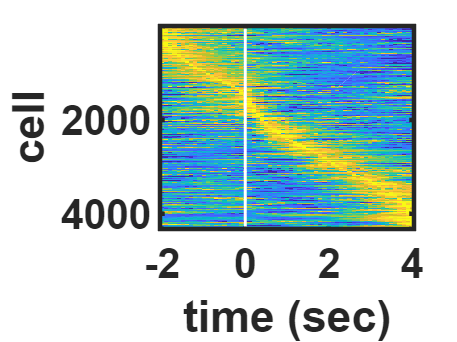

image_raw =     1.3574    1.3189    1.2617    1.1600    1.1590    1.0231    1.0222    1.3005    1.0627    1.1152    1.0116    1.0457    1.0703    0.9480    0.7943    0.8760    0.9018    0.8820    0.8187    0.7641    0.8843    1.2856    1.1633    0.9628    1.0359    0.7517    0.5573    0.1765    0.3373    0.2227   -0.0400    0.0123   -0.1007   -0.2202   -0.4211   -0.4325   -0.5154   -0.7841   -0.7842   -0.8100   -0.9058   -1.0024   -1.2989   -1.1039   -1.4154   -1.2002   -1.2628   -1.3062   -1.3166   -1.0759
    1.3847    1.3788    1.2702    1.1264    0.6588    0.7108    0.5459    0.5239    0.8886    0.0996   -0.1269    0.6257    0.5745    0.2860    0.0575    0.3749   -0.1361   -0.2640   -0.7520   -0.5812   -0.4689   -0.8416   -1.5338   -1.5936   -1.7969   -1.6922   -2.0884   -1.8170   -2.2914   -2.2192   -1.9576   -1.3570   -0.9950   -0.6655    0.0468    0.1314    0.9737    0.7688    0.7863    1.3723    1.1047    0.7716    1.2480    0.8907    0.9433    0.6863    0.5914    0.7275    0.7

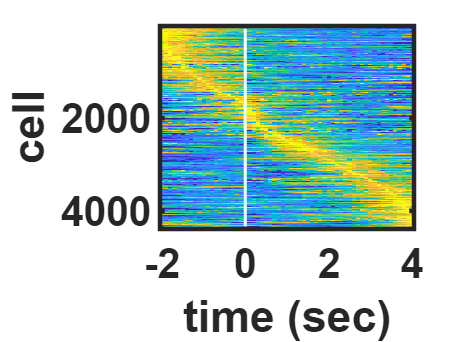

image_raw =     1.1856    0.9339    0.8596    1.0233    1.0176    1.1128    1.0925    1.0685    1.1466    1.1397    0.9102    0.6785    1.1432    0.8973    0.9838    0.7369    0.6491    0.5488    0.5701    0.7078    0.4931    0.2541    0.4301    0.8929    0.8419    0.5619    0.7460    0.5410    0.3495    0.2596    0.1717    0.0071   -0.1286    0.0287    0.3635    0.3437    0.3083    0.0176    0.2174    0.1122   -0.0496   -0.2080   -0.2398   -0.2567   -0.7191   -0.6806   -0.8522   -0.7859   -1.1333   -1.3553
    1.3002    1.2365    1.1787    1.1653    1.0182    0.9589    0.7655    0.8101    0.8106    0.6232    0.4803    0.6142    0.5594    0.5042    0.4371    0.3352    0.4381    0.8082    0.6480    0.5744    0.8185    0.9377    0.8748    1.0743    1.0069    1.0102    0.6864    0.7756    0.8290    0.4990    0.4511    0.6533    0.8824    0.4966    0.3315    0.2569    0.1199    0.0872   -0.3029   -0.3293   -0.3583   -0.5775   -0.7805   -0.9541   -0.8454   -0.8620   -0.9214   -1.0906   -1.0

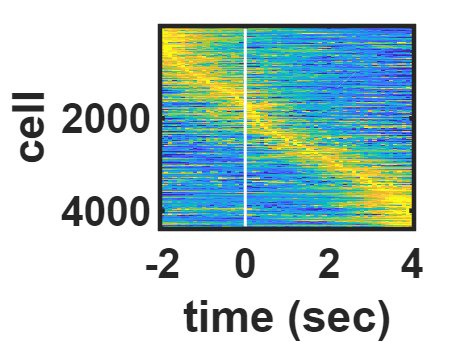

% plot neural activity heatmap
title_list = {'Reward', 'Reward miss', 'push_trial_push_prob_block', 'push_trial_pull_prob_block', 'pull_trial_push_prob_block', 'pull_trial_pull_prob_block',...
    'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block',...
    'push_trial_push_prob_block','push_trial_pull_prob_block','pull_trial_push_prob_block','pull_trial_pull_prob_block',...
    'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block'};
if norm == 1
    climit = [0 1];
elseif norm == 2 || norm == 3 || norm == 4 || norm == 5
    climit = [-2 2];
else
    climit = [0 20]; %[0 50];
end

for i = 1:length(eta_acts_conc)
    figure
    set(gcf,'color','w');
    % for i = 1:length(brain_roi) 
    %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
        clims = climit;
        image_raw = eta_acts_conc{i} %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        rows_to_remove = any(isnan(image_raw), 2);
        image = image_raw(~rows_to_remove,:);
        imagesc(-before_event:0.1:after_event,1:size(image,1),image,clims);
        ylabel('cell');
        xlabel('time (sec)')
    % end
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
    hold off;    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_' title_list{i} '_eta_activity_heatmap.png'];
    filename = [output_dir  '_' title_list{i} '_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;
end

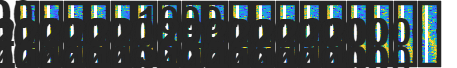

figure('Position', [100, 100, 4800, 600]);
set(gcf,'color','w');

for i = 1:length(eta_acts_conc) 
    subaxis(1,length(eta_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
    clims = climit;
    image_raw = eta_acts_conc{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    rows_to_remove = any(isnan(image_raw), 2);
    image = image_raw(~rows_to_remove,:);
    imagesc(-before_event:0.1:after_event,1:size(image,1),image,clims);    
%         ylabel('cell');
    xlabel('time (sec)');
    if i == 1
        ylabel('cell');
    end
    title(title_list{i});
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
    hold off;    
end
%     xlabel('time (sec)');

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' strrep(strjoin(title_list),' ','_') '_eta_activity_heatmap.png'];
filename = [output_dir 'all_conditions_eta_activity_heatmap.png'];
saveas(gcf,filename);

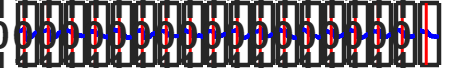


figure('Position', [100, 100, 4800, 600]);
for i = 1:length(eta_acts_conc)
    subaxis(1,length(eta_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
    % NaNを含む行を削除
    data = eta_acts_conc{i};
    data = data(~any(isnan(data), 2), :);
    z = zscore(data, 0, 1); % 列方向に Zスコアを計算
    data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

    mean_values = mean(data, 1);
    std_values = std(data, 0, 1);
    x = -before_event:0.1:after_event;
  
    % fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
    hold on;
    plot(x, mean_values, 'b', 'LineWidth', 1.5); 
    % xlim = [-2,4]
    % x=0に赤い縦線をプロット       
    % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    if norm ~= 0
        plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
    else
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
    end
    hold off;
    if i == 1;
        ylabel('normalized activity');
    end
    xlabel('time (sec)');
    title(title_list{i});        
     axis tight;
    if norm ~= 0 & norm ~= 6
        ylim([-1 1]);  
    elseif norm == 6
        ylim([-1 6]); %ylim([-1 2]);
    end
end
    
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity.png'];
filename = [output_dir 'all_conditions_eta_activity.png'];
saveas(gcf,filename);

% figure('Position', [100, 100, 1000, 600]);
% num_plots = length(eta_acts_conc) / 2;  % 2つずつ重ねるので実プロット数は半分
% 
% for i = 1:num_plots
%     subaxis(1, num_plots, i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.08);
%     hold on;
%     x = -before_event:0.1:after_event;
% 
%     for j = 0:1  % j=0→奇数番目, j=1→偶数番目
%         idx = (i - 1) * 2 + j + 1;
%         data = eta_acts_conc{idx};
%         data = data(~any(isnan(data), 2), :);
%         z = zscore(data, 0, 1); % 列方向に Zスコアを計算
%         data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去
%         mean_values = mean(data, 1);
% 
%         % 破線か実線か（偶数番号は破線）
%         if mod(idx, 2) == 0
%             color = [0.5 0.5 0.5];
%         else
%             color = 'k';
%         end
% 
%         % 白黒プロット（グレーにしたければ [0.5 0.5 0.5] などでも可）
%         plot(x, mean_values, 'Color', color, 'LineStyle', '-', 'LineWidth', 3);
%     end
% 
%     % x=0 に赤い縦線
%     if norm ~= 0
%         plot([0 0], [-100, 100], 'k--', 'LineWidth', 2);      
%     else
%         yLimits = get(gca, 'YLim');
%         plot([0 0], yLimits, 'k--', 'LineWidth', 2);
%     end
% 
%     % 軸やラベル
%     if i == 1
%         ylabel('normalized activity');
%     end
%     xlabel('time (sec)');
%     title([title_list{(i-1)*2+1} ' + ' title_list{(i-1)*2+2}]);
% 
%     axis tight;
%     if norm ~= 0 && norm ~= 6
%         ylim([-1 1]);  
%     elseif norm == 6
%         ylim([-1 3]);
%     end
%     hold off;
% end
% 
% % 保存
% filename = [output_dir strrep(strjoin(title_list),' ','_') '_eta_activity_DC.png'];
% saveas(gcf, filename);


% write eta code by categrizing neurons by layers
if categorize == 'layer' 
    eta_layer23_acts_conc = cell(1, length(eta_acts));
    eta_layer5_acts_conc = cell(1, length(eta_acts));
    for i = 1:length(eta_acts)
        % % align concatenated eta neural activities
        % [M,eta_i] = max(eta_acts_conc{i},[],2);
        % if norm==3
        %     eta_acts_conc{i} = cat(2, eta_i,pointAreas_conc(find(sig_cell_idxs2_conc{i} == 1)) ,eta_acts_conc{i});
        % else
        %     eta_acts_conc{i} = cat(2, eta_i,pointAreas_conc ,eta_acts_conc{i});
        % end        
        % eta_acts_conc{i} =   sortrows(eta_acts_conc{i});
        % eta_acts_max_act_times_conc{i} = eta_acts_conc{i}(:,1)/10 -2;
        % etaAreas = eta_acts_conc{i}(:,2);
        % eta_acts_conc{i}(:,1:2) = [];
        % specify layer specific activity
        eta_layer23_acts_conc{i} = eta_acts_conc{i}(find(sortedAreas_conc{i} == 1),:);
        eta_layer5_acts_conc{i}  = eta_acts_conc{i}(find(sortedAreas_conc{i} == 0),:);        
        % eta_layer23_acts_conc{i} = eta_acts_conc{i}(find(etaAreas == 1),:);
        % eta_layer5_acts_conc{i}  = eta_acts_conc{i}(find(etaAreas == 0),:);
    end
end

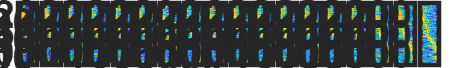

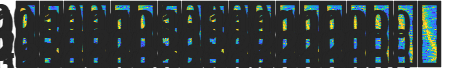

% plot layer specific eta by multiple plane figure
if categorize == 'layer'
    figure('Position', [100, 100, 4800, 600])
    set(gcf,'color','w');
    for i = 1:length(eta_layer23_acts_conc) 
        subaxis(1,length(eta_layer23_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
        clims = climit;      
        image_raw = eta_layer23_acts_conc{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        rows_to_remove = any(isnan(image_raw), 2);
        image = image_raw(~rows_to_remove,:);
        imagesc(-before_event:0.1:after_event,1:size(image,1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     xlabel('time (sec)');
   
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' strrep(strjoin(title_list),' ','_') '_layer23_eta_activity_heatmap.png'];
    filename = [output_dir 'all_conditions_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
    
    figure('Position', [100, 100, 4800, 600])
    set(gcf,'color','w');
    for i = 1:length(eta_layer5_acts_conc) 
        subaxis(1,length(eta_layer5_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
        clims = climit;
        image_raw = eta_layer5_acts_conc{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        rows_to_remove = any(isnan(image_raw), 2);
        image = image_raw(~rows_to_remove,:);
        imagesc(-before_event:0.1:after_event,1:size(image,1),image,clims);        
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     ylabel('cell');
    filename = [output_dir  'all_conditions_layer5_eta_activity_heatmap.png'];
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' strrep(strjoin(title_list),' ','_')  '_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
end

% % plot pie graph
% if norm ==3
%     high_low_reward_idx = sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6};
%     high_reward_idx     = sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6};
%     low_reward_idx      = ~sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6};
%     neither_idx         = ~sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6}; 
%     for i_animal = 2:length(Animal)
%         high_low_reward_idx = [high_low_reward_idx, sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6}];
%         high_reward_idx     = [high_reward_idx, sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6}];
%         low_reward_idx      = [low_reward_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6}];
%         neither_idx         = [neither_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6}]; 
%     end
% 
%     data = [sum(high_low_reward_idx) sum(high_reward_idx) sum(low_reward_idx) sum(neither_idx)]
%     labels = {'high and low reward','high reward','low reward', 'neither'};
%     figure
%     % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
%     p = pie(data); %, labels);
%     % title({'Percentage of neurons that reflect value among the neurons ', 'that fire when force is applied. (n=143)'});
%     pText = findobj(p,'Type','text');
%     percentValues = get(pText,'String');
%     txt = {['(' num2str(data(1)) ')']; ['(' num2str(data(2)) ')']; ['(' num2str(data(3)) ')']; ['(' num2str(data(4)) ')']};
%     combinedtxt = strcat(percentValues,txt);
%     pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
%     pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
%     legend(labels,'Location','southoutside'); 
% 
%     filename = [output_dir  strrep(strjoin(title_list),' ','_'), '_' categorize '_action_value_cells_pie.png'];
%     % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' strrep(strjoin(title_list),' ','_'), '_' categorize '_action_value_cells_pie.png'];
%     saveas(gcf,filename);
% end

% if norm == 3 & strcmp(categorize, 'layer')
%     pointAreas_session = pointAreas_all_sessions{1};
%     pointAreas_logical = logical(pointAreas_session');
%     high_low_reward_layer23_idx = sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6} & pointAreas_logical;
%     high_reward_layer23_idx     = sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6} & pointAreas_logical;
%     low_reward_layer23_idx      = ~sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6} & pointAreas_logical;
%     neither_layer23_idx         = ~sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6} & pointAreas_logical;   
%     high_low_reward_layer5_idx = sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6} & ~pointAreas_logical;
%     high_reward_layer5_idx     = sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6} & ~pointAreas_logical;
%     low_reward_layer5_idx      = ~sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6} & ~pointAreas_logical;
%     neither_layer5_idx         = ~sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6} & ~pointAreas_logical;
%     for i_animal = 2:length(Animal)  
%         pointAreas_session = pointAreas_all_sessions{i_animal};
%         pointAreas_logical = logical(pointAreas_session');        
%         high_low_reward_layer23_idx = [high_low_reward_layer23_idx, sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6} & pointAreas_logical];
%         high_reward_layer23_idx     = [high_reward_layer23_idx, sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6} & pointAreas_logical];
%         low_reward_layer23_idx      = [low_reward_layer23_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6} & pointAreas_logical];
%         neither_layer23_idx         = [neither_layer23_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6} & pointAreas_logical];   
%         high_low_reward_layer5_idx = [high_low_reward_layer5_idx, sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6} & ~pointAreas_logical];
%         high_reward_layer5_idx     = [high_reward_layer5_idx, sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6} & ~pointAreas_logical];
%         low_reward_layer5_idx      = [low_reward_layer5_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6} & ~pointAreas_logical];
%         neither_layer5_idx         = [neither_layer5_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6} & ~pointAreas_logical]; 
%     end
% 
%     data_layer23 = [sum(high_low_reward_layer23_idx) sum(high_reward_layer23_idx) sum(low_reward_layer23_idx) sum(neither_layer23_idx)];
%     data_layer5 = [sum(high_low_reward_layer5_idx) sum(high_reward_layer5_idx) sum(low_reward_layer5_idx) sum(neither_layer5_idx)];
%     labels = {'high and low reward','high reward','low reward', 'neither'};
% 
%     figure
% 
%     % Layer 23 の円グラフを左側にプロット
%     subplot(1, 2, 1);  % 1行2列のグラフのうち、左側にプロット
%     p23 = pie(data_layer23); layer_proportions
%     pText23 = findobj(p23, 'Type', 'text');
%     percentValues23 = get(pText23, 'String');
%     txt23 = {['(' num2str(data_layer23(1)) ')']; ['(' num2str(data_layer23(2)) ')']; ['(' num2str(data_layer23(3)) ')']; ['(' num2str(data_layer23(4)) ')']};
%     combinedtxt23 = strcat(percentValues23, txt23);
%     for i = 1:length(pText23)
%         pText23(i).String = combinedtxt23{i}; 
%     end
%     title('Layer 23');
%     legend(labels, 'Location', 'southoutside');
% 
%     % Layer 5 の円グラフを右側にプロット
%     subplot(1, 2, 2);  % 1行2列のグラフのうち、右側にプロット
%     p5 = pie(data_layer5); 
%     pText5 = findobj(p5, 'Type', 'text');
%     percentValues5 = get(pText5, 'String');
%     txt5 = {['(' num2str(data_layer5(1)) ')']; ['(' num2str(data_layer5(2)) ')']; ['(' num2str(data_layer5(3)) ')']; ['(' num2str(data_layer5(4)) ')']};
%     combinedtxt5 = strcat(percentValues5, txt5);
%     for i = 1:length(pText5)
%         pText5(i).String = combinedtxt5{i}; 
%     end
%     title('Layer 5');
%     legend(labels, 'Location', 'southoutside');
% 
%     % 保存
%     filename = [output_dir strrep(strjoin(title_list),' ','_'), '_' categorize '_action_value_cells_layer_pie.png'];    
%     % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_action_value_cells_layer_pie.png'];
%     saveas(gcf, filename);
% end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
if strcmp(categorize, 'layer') == 1
    % title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    % figure('Position', [100, 100, 2400, 600]);
    % set(gcf,'color','w');
    % for i = 1:length(AlinmentTimingCells)
    %     subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
    %     clims = climit;
    %     image = pull_act_layer23_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    %     % NaNを含む行を削除
    %     image = image(~any(isnan(image), 2), :);
    %     imagesc(-before_event:0.1:after_event,1:size(pull_act_layer23_cells{i},1),image,clims);
    %     if i == 1
    %         ylabel('cell');
    %     end
    %     xlabel('time (sec)');
    %     title(title_list{i});
    %     % x=0 に白い縦線を描画
    %     hold on; % プロットを追加するために hold on を使用
    %     yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    %     plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
    %     hold off;           
    % end
    % 
    % % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer23_eta_activity_heatmap.png'];
    % filename = [output_dir 'pull_layer23_eta_activity_heatmap.png'];
    % saveas(gcf,filename);
    % % close all;
    % 
    figure('Position', [100, 100, 4800, 600]);
    for i = 1:length(eta_layer23_acts_conc)
        subaxis(1,length(eta_layer23_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
        % NaNを含む行を削除
        data = eta_layer23_acts_conc{i};
        data = data(~any(isnan(data), 2), :);
        z = zscore(data, 0, 1); % 列方向に Zスコアを計算
        data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);      
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end      
        hold off;
        axis tight;  
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});

    end

    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer23_eta_activity.png'];
    filename = [output_dir  'layer23_eta_activity_conc.png'];
    saveas(gcf,filename);
    % close all;
    % 
    % figure('Position', [100, 100, 2400, 600]);
    % set(gcf,'color','w');
    % for i = 1:length(AlinmentTimingCells)
    %     subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
    %     clims = climit;
    %     image = pull_act_layer5_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    %     % NaNを含む行を削除
    %     image = image(~any(isnan(image), 2), :);        
    %     imagesc(-before_event:0.1:after_event,1:size(pull_act_layer5_cells{i},1),image,clims);
    %     % x=0 に白い縦線を描画
    %     hold on; % プロットを追加するために hold on を使用
    %     yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    %     plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
    %     hold off;          
    %     if i == 1
    %         ylabel('cell');
    %     end
    %     xlabel('time (sec)');
    %     title(title_list{i});
    % end
    % 
    % % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer5_eta_activity_heatmap.png'];
    % filename = [output_dir 'pull_layer5_eta_activity_heatmap.png'];
    % saveas(gcf,filename);
    % % close all;

    figure('Position', [100, 100, 4800, 600]);
    for i = 1:length(eta_layer5_acts_conc)
        subaxis(1,length(eta_layer5_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
        % NaNを含む行を削除
        data = eta_layer5_acts_conc{i};
        data = data(~any(isnan(data), 2), :);
        z = zscore(data, 0, 1); % 列方向に Zスコアを計算
        data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);              
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end       
        hold off;
        axis tight;          
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end     
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer5_eta_activity.png'];
    filename = [output_dir 'layer5_eta_activity_conc.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 4800, 600]);
    for i = 1:length(eta_layer23_acts_conc)
        subaxis(1,length(eta_layer23_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
        % NaNを含む行を削除
        data23 = eta_layer23_acts_conc{i};
        data23 = data23(~any(isnan(data23), 2), :);
        data5 = eta_layer5_acts_conc{i};
        data5 = data5(~any(isnan(data5), 2), :);        
        z23 = zscore(data23, 0, 1); z5 = zscore(data5, 0, 1); % 列方向に Zスコアを計算
        data23 = data23(max(abs(z23), [], 2) < 10, :);data5 = data5(max(abs(z5), [], 2) < 10, :); % Zスコアが100以上の行を除去

        % mean_values = mean(data, 1);
        % std_values = std(data, 0, 1);              
        mean_values23 = mean(data23, 1);
        std_values23 = std(data23, 0, 1);        
        mean_values5 = mean(data5, 1);
        std_values5 = std(data5, 0, 1);
        x = -before_event:0.1:after_event;

        hold on;        
        fill([x, fliplr(x)], [mean_values23 + std_values23, fliplr(mean_values23 - std_values23)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values23, 'g', 'LineWidth', 1.5); 
        fill([x, fliplr(x)], [mean_values5 + std_values5, fliplr(mean_values5 - std_values5)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values5, 'b', 'LineWidth', 1.5);         
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end        
        hold off;
        axis tight;  
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end      
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer235_eta_activity.png'];
    filename = [output_dir 'pull_layer235_eta_activity.png'];
    saveas(gcf,filename);
    close all;
end

%% 7. タイムウィンドウ分離による Prior vs Action 選択性の抽出

fprintf('\n========== Time-Window Separated Preference Analysis ==========\n');


========== Time-Window Separated Preference Analysis ==========


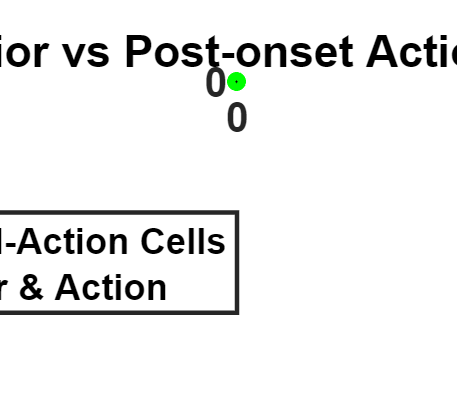


% --- 時間窓（Time Window）の設定 ---
% fps = 10, before_event = 2 (20フレーム目が0秒直前、21フレーム目が0秒)
idx_zero = fps * before_event + 1;
pre_window  = (idx_zero - fps) : idx_zero;      % イベント前 -1.0秒 ～ 0秒
post_window = idx_zero : (idx_zero + fps);      % イベント後  0秒 ～ +1.0秒

threshold_pref = 0.5; % 有意な選択性とみなすZ-scoreの差分閾値

% --- 2x2 条件のデータを取得 ---
% 3: PushAction/PushPrior, 4: PushAction/PullPrior, 5: PullAction/PushPrior, 6: PullAction/PullPrior
act_push_priorPush = eta_acts_conc{3};
act_push_priorPull = eta_acts_conc{4};
act_pull_priorPush = eta_acts_conc{5};
act_pull_priorPull = eta_acts_conc{6};

% =========================================================================
% 1. Pre-onset における Prior 選択性の計算
% =========================================================================
% イベント前の活動を平均
pre_push_priorPush = mean(act_push_priorPush(:, pre_window), 2, 'omitnan');
pre_push_priorPull = mean(act_push_priorPull(:, pre_window), 2, 'omitnan');
pre_pull_priorPush = mean(act_pull_priorPush(:, pre_window), 2, 'omitnan');
pre_pull_priorPull = mean(act_pull_priorPull(:, pre_window), 2, 'omitnan');

% 実際の行動(Action)を平均化して相殺し、Priorの主効果を出す
pre_prior_pull = (pre_push_priorPull + pre_pull_priorPull) / 2;
pre_prior_push = (pre_push_priorPush + pre_pull_priorPush) / 2;

% Prior Index (正: Pull期待で活動UP, 負: Push期待で活動UP)
prior_idx_pre = pre_prior_pull - pre_prior_push;

% =========================================================================
% 2. Post-onset における Action 選択性の計算
% =========================================================================
% イベント後の活動を平均
post_push_priorPush = mean(act_push_priorPush(:, post_window), 2, 'omitnan');
post_push_priorPull = mean(act_push_priorPull(:, post_window), 2, 'omitnan');
post_pull_priorPush = mean(act_pull_priorPush(:, post_window), 2, 'omitnan');
post_pull_priorPull = mean(act_pull_priorPull(:, post_window), 2, 'omitnan');

% Prior(文脈)を平均化して相殺し、Actionの主効果を出す
post_action_pull = (post_pull_priorPush + post_pull_priorPull) / 2;
post_action_push = (post_push_priorPush + post_push_priorPull) / 2;

% Action Index (正: 実際のPullで活動UP, 負: 実際のPushで活動UP)
action_idx_post = post_action_pull - post_action_push;

% =========================================================================
% 3. 細胞の分類と特定
% =========================================================================
% A. Pull Priorのみに反応する細胞 (Pull期待でPreに発火するが、Postの実際の運動方向には無関心)
idx_pullPrior_only = (prior_idx_pre > threshold_pref) & (abs(action_idx_post) < threshold_pref);

% B. Pull Actionのみに反応する細胞 (Preの期待には無関心だが、Postで実際にPullすると発火)
idx_pullAction_only = (abs(prior_idx_pre) < threshold_pref) & (action_idx_post > threshold_pref);

% C. Push Priorのみに反応する細胞
idx_pushPrior_only = (prior_idx_pre < -threshold_pref) & (abs(action_idx_post) < threshold_pref);

% D. 期待(Pull)通りに引いた(Pull)細胞 (Congruent: 両方でプラス)
idx_congruent_pull = (prior_idx_pre > threshold_pref) & (action_idx_post > threshold_pref);

% =========================================================================
% 4. 散布図のプロット
% =========================================================================
figure('Name', 'Temporal Separation: Pre-Prior vs Post-Action', 'Color', 'w', 'Position', [150, 150, 800, 700]);
hold on;

% 全細胞 (グレー)
scatter(action_idx_post, prior_idx_pre, 25, 'filled', 'MarkerFaceColor', [0.8 0.8 0.8], 'MarkerFaceAlpha', 0.5);

% Pull Priorのみ (赤) - ★あなたが探している細胞★
scatter(action_idx_post(idx_pullPrior_only), prior_idx_pre(idx_pullPrior_only), 40, 'r', 'filled');

% Pull Actionのみ (青)
scatter(action_idx_post(idx_pullAction_only), prior_idx_pre(idx_pullAction_only), 40, 'b', 'filled');

% 両方に応答 (緑)
scatter(action_idx_post(idx_congruent_pull), prior_idx_pre(idx_congruent_pull), 40, 'g', 'filled');

% 軸と枠線の設定
max_val = max(abs([action_idx_post; prior_idx_pre]), [], 'omitnan') + 0.2;
if isempty(max_val) || isnan(max_val), max_val = 2; end
xlim([-max_val max_val]); ylim([-max_val max_val]);
axis square; grid on;

xline(0, 'k-', 'LineWidth', 1.0); yline(0, 'k-', 'LineWidth', 1.0);
plot([-threshold_pref -threshold_pref], ylim, 'k:'); plot([threshold_pref threshold_pref], ylim, 'k:');
plot(xlim, [-threshold_pref -threshold_pref], 'k:'); plot(xlim, [threshold_pref threshold_pref], 'k:');

xlabel('Action Preference in POST-onset (Z-score Diff: Pull > 0 > Push)', 'FontWeight', 'bold');
ylabel('Prior Preference in PRE-onset (Z-score Diff: PullBlock > 0 > PushBlock)', 'FontWeight', 'bold');
title('Pre-onset Prior vs Post-onset Action Preference');

legend('Unselective / Others', 'Pure Pull-Prior Cells (Target)', 'Pure Pull-Action Cells', 'Pull Prior & Action', 'Location', 'southoutside', 'NumColumns', 2);

hold off;
saveas(gcf, [output_dir 'Temporal_Prior_vs_Action_Scatter.png']);


% =========================================================================
% 5. 結果の出力とインデックスの保存
% =========================================================================
fprintf('\n[Classification Results: threshold = %.1f Z-score]\n', threshold_pref);


[Classification Results: threshold = 0.5 Z-score]


total_valid = sum(~isnan(prior_idx_pre) & ~isnan(action_idx_post));
fprintf('Total Valid Cells: %d\n', total_valid);

Total Valid Cells: 4035



% 探している細胞の数
n_target = sum(idx_pullPrior_only);
fprintf('★ Pure Pull-Prior Cells (Active before Pull, no action bias): %d (%.1f%%)\n', n_target, n_target/total_valid*100);

★ Pure Pull-Prior Cells (Active before Pull, no action bias): 395 (9.8%)



% 該当する細胞の通し番号(全体インデックス)を取得して表示
target_cell_list = find(idx_pullPrior_only);
fprintf(' -> Cell Indices: ');

 -> Cell Indices: 

disp(target_cell_list');

           6          16          24          25          64          66          70          71          85         102        8182        8183        8184        8185        8195        8203        8229        8254        8267        8269        8271        8274        8277        8281        8283        8287        8290        8302        8315        8320        8342        8351        8358        8362        8367        8372        8376        8382        8420        8425        8430        8436        8448        8458        8459        8463        8466        8467        8468        8474        8477        8485        8487        8489        8490        8505        8516        8524        8532        8536        8542        8549        8556        8560        8571        8581        8587        8592        8601        8606        8609        8643        8644        8649        8655        8657        8662        8679        8684        8690        8707        8711        8713    


% MATLABワークスペースに細胞リストを保存（後で波形を描画するため）
% save([output_dir 'Pure_Pull_Prior_Cells.mat'], 'target_cell_list', 'prior_idx_pre', 'action_idx_post');

%% 8. 特定されたターゲット細胞の ETA 波形プロット

fprintf('\n========== Plotting ETA for Target Cells ==========\n');


========== Plotting ETA for Target Cells ==========


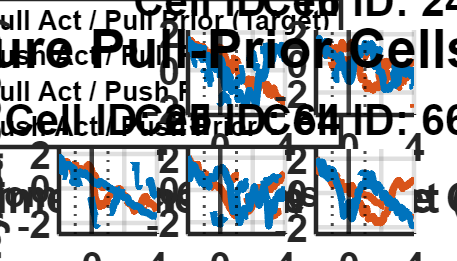

Target cells ETA plots saved: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1369_rbp4c1377_rbp4c1379_rbp4c1384_norm2_inside_trial_eta2/TargetCells_4Condition_ETA.png



% 前のブロックで取得したリストを使用
% target_cell_list = find(idx_pullPrior_only); 

if isempty(target_cell_list)
    fprintf('対象となる細胞が見つかりませんでした。\n');
else
    % プロットする細胞数を決定（最大6細胞）
    num_plot_cells = min(6, length(target_cell_list));
    
    % 先頭から選ぶ場合（ランダムに選びたい場合は以下のコメントアウトを外す）
    % rng('shuffle'); % 乱数シード初期化
    % plot_cells = target_cell_list(randperm(length(target_cell_list), num_plot_cells));
    plot_cells = target_cell_list(1:num_plot_cells);
    
    % 時間軸の作成 (例: fps=10, before=2, after=4 なら -2:0.1:4)
    time_axis = -before_event : (1/fps) : after_event; 
    
    figure('Name', 'Target Cells ETA', 'Color', 'w', 'Position', [100, 100, 1400, 800]);
    
    for i = 1:num_plot_cells
        c_idx = plot_cells(i);
        
        subplot(2, 3, i); hold on;
        
        % 各条件の波形を抽出 (eta_acts_conc から該当行を取得)
        % 3: Push Act / Push Prior
        % 4: Push Act / Pull Prior
        % 5: Pull Act / Push Prior
        % 6: Pull Act / Pull Prior
        trace_pushAct_pushPrior = eta_acts_conc{3}(c_idx, :);
        trace_pushAct_pullPrior = eta_acts_conc{4}(c_idx, :);
        trace_pullAct_pushPrior = eta_acts_conc{5}(c_idx, :);
        trace_pullAct_pullPrior = eta_acts_conc{6}(c_idx, :);
        
        % =========================================================
        % プロット (線種と色のルール)
        % 【色】  Prior=Pull: 赤系, Prior=Push: 青系
        % 【線種】Action=Pull: 実線, Action=Push: 破線
        % =========================================================
        p1 = plot(time_axis, trace_pullAct_pullPrior, 'Color', [0.85 0.33 0.10], 'LineWidth', 2.5, 'LineStyle', '-');  % 赤・実線
        p2 = plot(time_axis, trace_pushAct_pullPrior, 'Color', [0.85 0.33 0.10], 'LineWidth', 2.5, 'LineStyle', '--'); % 赤・破線
        p3 = plot(time_axis, trace_pullAct_pushPrior, 'Color', [0.00 0.45 0.74], 'LineWidth', 2.5, 'LineStyle', '-');  % 青・実線
        p4 = plot(time_axis, trace_pushAct_pushPrior, 'Color', [0.00 0.45 0.74], 'LineWidth', 2.5, 'LineStyle', '--'); % 青・破線
        
        % --- 装飾 ---
        % Force Onset (0秒)
        xline(0, 'k-', 'LineWidth', 1.5); 
        
        % 解析に用いた Pre/Post のタイムウィンドウ(-1s と +1s) を点線で示す
        xline(-1, 'k:', 'LineWidth', 1.0); 
        xline(1,  'k:', 'LineWidth', 1.0); 
        
        title(sprintf('Cell ID: %d', c_idx), 'FontSize', 14);
        xlabel('Time from Force Onset (s)', 'FontSize', 12);
        if i == 1 || i == 4
            ylabel('Activity (Z-score)', 'FontSize', 12);
        end
        
        % 軸の調整
        y_max = max([trace_pullAct_pullPrior, trace_pushAct_pullPrior, trace_pullAct_pushPrior, trace_pushAct_pushPrior], [], 'omitnan') + 0.5;
        y_min = min([trace_pullAct_pullPrior, trace_pushAct_pullPrior, trace_pullAct_pushPrior, trace_pushAct_pushPrior], [], 'omitnan') - 0.5;
        if ~isempty(y_max) && ~isnan(y_max), ylim([y_min y_max]); end
        xlim([-before_event after_event]);
        
        % 最初のサブプロットだけ凡例を表示
        if i == 1
            legend([p1, p2, p3, p4], ...
                {'Pull Act / Pull Prior (Target)', ...
                 'Push Act / Pull Prior', ...
                 'Pull Act / Push Prior', ...
                 'Push Act / Push Prior'}, ...
                'Location', 'best', 'FontSize', 9);
        end
        grid on; box off;
    end
    
    sgtitle('ETA of Pure Pull-Prior Cells (Target)', 'FontSize', 18, 'FontWeight', 'bold');
    
    % 保存
    output_name = [output_dir 'TargetCells_4Condition_ETA.png'];
    saveas(gcf, output_name);
    fprintf('Target cells ETA plots saved: %s\n', output_name);
end

% 階層的クラスタリングの実施

% 1. すべての要素が NaN であるセルを特定して除外
% cellfun を使用して、各行列の全要素が NaN かどうかを判定します
is_all_nan = cellfun(@(x) all(isnan(x(:))), eta_acts_conc);
is_all_nan(1) = 1; is_all_nan(2) = 1;%temporaly
filtered_eta_acts = eta_acts_conc(~is_all_nan);

if isempty(filtered_eta_acts)
    error('有効な ETA データがありません。すべてのデータが NaN です。');
end

fprintf('除外された NaN イベント数: %d / %d\n', sum(is_all_nan), length(eta_acts_conc));

除外された NaN イベント数: 2 / 18


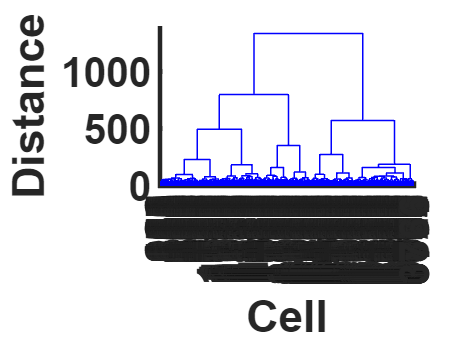


% 2. 有効なデータのみを横方向に結合
try
    data_all = horzcat(filtered_eta_acts{:});
catch
    error('有効なデータ間で細胞数（行数）が一致していないため、横方向に結合できません。');
end

% 3. 特定の行（細胞）に一部でも NaN が含まれる場合はその行を削除
% (例：特定の細胞だけ解析期間外だった場合など)
nan_rows = any(isnan(data_all), 2); 
data = data_all(~nan_rows, :);

% メタデータ (pointAreas) のフィルタリング
if iscell(pointAreas_conc)
    pointAreas_combined = vertcat(pointAreas_conc{:}); % セルなら結合
else
    pointAreas_combined = pointAreas_conc; % 行列ならそのまま
end
pointAreas_filtered = pointAreas_combined(~nan_rows, :);
% 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
linkage_matrix = linkage(data, 'ward');

% 樹形図の作成
figure('Position', [100, 100, 800, 600]);
[H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
% title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
xlabel('Cell');
ylabel('Distance');
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_hierarchical_clustering_dendrogram.png'];
filename = [output_dir 'hierarchical_clustering_dendrogram_eta_conc.png'];
saveas(gcf,filename);    

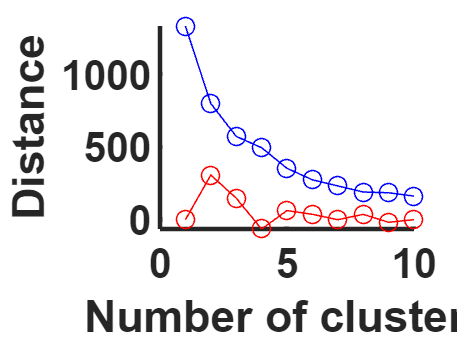


% 順序付けされたdata
ordered_data = data(outperm, :);

% エルボー法のためのプロット作成
figure('Position', [100, 100, 800, 600]);
last = linkage_matrix(end-9:end, 3);
last_rev = flipud(last);
indexes = 1:length(last);
hold on
plot(indexes, last_rev, 'b-o');
acceleration = diff(last, 2);  % 2次の微分を計算
acceleration_rev = zeros(10,1);
acceleration_rev(2:end-1) = flipud(acceleration);
plot(indexes, acceleration_rev, 'r-o');
hold off
xlabel('Number of clusters');
ylabel('Distance');
% title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_elbow.png'];
filename = [output_dir 'elbow_eta_conc.png'];
saveas(gcf,filename);     

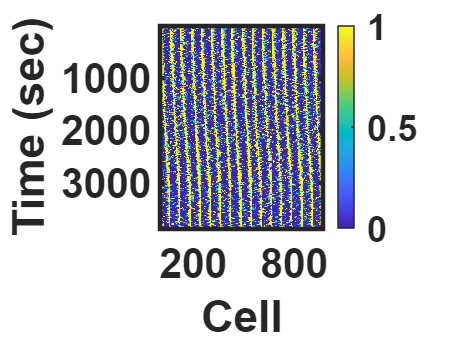


% 相関行列の表示
figure('Position', [100, 100, 800, 600]);
imagesc(ordered_data, [0 1]);
colorbar;
% title(title_list{i});  %title('Correlation Matrix');
xlabel('Cell');
ylabel('Time (sec)');
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_eta_heatmap2.png'];
filename = [output_dir 'eta_heatmap2_conc.png'];
saveas(gcf,filename);         

    % colormap('viridis');
% end

% plot clustered ETA neural activity
num_clusters = 8; % クラスター数を指定（必要に応じて変更）

title_list = {'Reward', 'Reward miss', 'push_trial_push_prob_block_pull', 'push_trial_pull_prob_block_pull', 'pull_trial_push_prob_block_pull', 'pull_trial_pull_prob_block_pull',...
    'push_trial_push_value_block_pull','push_trial_pull_value_block_pull','pull_trial_push_value_block_pull','pull_trial_pull_value_block_pull',...
    'push_trial_push_prob_block_push','push_trial_pull_prob_block_push','pull_trial_push_prob_block_push','pull_trial_pull_prob_block_push',...
    'push_trial_push_value_block_push','push_trial_pull_value_block_push','pull_trial_push_value_block_push','pull_trial_pull_value_block_push'};
% title_list = {'Reward', 'Reward miss', 'Force usual resistance', 'Force rare resistance', 'Force high reward', 'Force low reward'};

% 1. 全てNaNの要素を除外したリストの作成（クラスタリング時と同じ論理インデックスを使用）
is_all_nan = cellfun(@(x) all(isnan(x(:))), eta_acts_conc);
is_all_nan(1) = 1; is_all_nan(2) = 1; %temporaly
valid_eta_acts = eta_acts_conc(~is_all_nan);
valid_titles = title_list(~is_all_nan);
num_valid_events = length(valid_eta_acts);

% --- 階層的クラスタリングの実行 ---
cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
all_cluster_labels = cluster_labels;
unique_elements = unique(cluster_labels);
counts = histc(cluster_labels, unique_elements);

for n = 1:length(unique_elements)
    fprintf('Cluster %d: %d cells\n', unique_elements(n), counts(n));
end

Cluster 1: 323 cells
Cluster 2: 586 cells
Cluster 3: 315 cells
Cluster 4: 362 cells
Cluster 5: 319 cells
Cluster 6: 407 cells
Cluster 7: 653 cells
Cluster 8: 922 cells


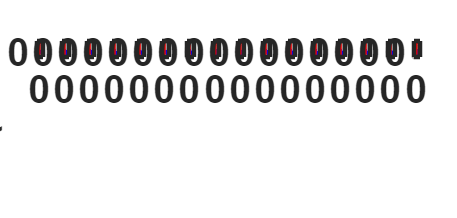


% --- プロットの実行 ---
% 横方向にイベント（有効なもののみ）、縦方向にクラスタを配置
fig_width = 400 * num_valid_events; % イベント数に応じて横幅を調整
fig_height = 300 * num_clusters;    % クラスタ数に応じて縦幅を調整
figure('Position', [100, 100, min(fig_width, 2500), min(fig_height, 1200)], 'Color', 'w');

for i = 1:num_valid_events
    i_data = valid_eta_acts{i}; % 有効なデータセットを選択
    
    for cluster_num = 1:num_clusters   
        % サブプロットのインデックス計算: (行, 列, 現在の場所)
        % 有効なイベント数 (num_valid_events) に基づいて配置
        subaxis(num_clusters, num_valid_events, i + num_valid_events*(cluster_num-1), ...
            'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        
        % 現在のクラスタに属する細胞のデータを抽出
        % ※ cluster_labels は全細胞に対するもの。横方向結合データからNaN行を除去した後の順序と一致している必要があります
        cluster_data = i_data(cluster_labels == cluster_num, :);
        
        % 行内（トライアル平均波形）にNaNが含まれる場合は除去
        cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
        
        if isempty(cluster_data)
            axis off; continue;
        end

        % 外れ値除去 (Z-score 10以上を除去)
        if size(cluster_data, 1) > 1
            z = zscore(cluster_data, 0, 1);
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :);
        end

        % 統計値の計算
        mean_values = mean(cluster_data, 1);
        std_values = std(cluster_data, 0, 1);
        x = -before_event:0.1:after_event;
      
        % 平均 ± 標準偏差 の塗りつぶし
        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], ...
             'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.2); 
        
        % イベント発生時刻 (x=0) の縦線
        if norm ~= 0
            plot([0 0], [-100, 100], 'r-', 'LineWidth', 1);     
        else
            yLimits = ylim;
            plot([0 0], yLimits, 'r-', 'LineWidth', 1);
        end
        hold off;

        % 軸ラベル・タイトルの設定
        if i == 1
            ylabel(sprintf('Cluster %d\n(z-score)', cluster_num), 'FontWeight', 'bold');
        end
        if cluster_num == num_clusters
            xlabel('time (sec)');
        end
        if cluster_num == 1
            % 有効なタイトルのみを反映
            title(valid_titles{i}, 'Interpreter', 'none', 'FontSize', 9);
        end
        
        % 表示範囲の固定
        axis tight;
        if norm ~= 0 && norm ~= 6
            ylim([-1.5 2.5]); % z-scoreの場合の標準的な範囲
        elseif norm == 6
            ylim([-6 24]);
        end
        grid on;
    end
end

% 保存
filename = [output_dir 'clustered_eta_valid_events_only.png'];
saveas(gcf, filename);

fprintf('Plot saved: %s\n', filename);

Plot saved: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1369_rbp4c1377_rbp4c1379_rbp4c1384_norm2_inside_trial_eta2/clustered_eta_valid_events_only.png


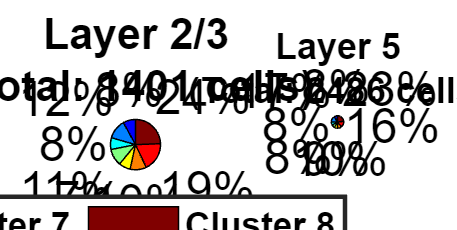

% --- クラスター分布の層別 Pie チャート作成 ---

% cluster_labels: フィルタリング後の各細胞のクラスター番号 (1 ~ num_clusters)
% pointAreas_filtered: フィルタリング後の各細胞の所属層 (1: L2/3, 0: L5)

unique_clusters = 1:num_clusters;
cluster_colors = jet(num_clusters); % クラスター間で共通の色を使用

figure('Name', 'Cluster Distribution by Layer', 'Position', [100, 100, 1100, 550], 'Color', 'w');

% --- 1. Layer 2/3 の解析とプロット ---
subplot(1, 2, 1);
idx_l23 = (pointAreas_filtered == 1);
if any(idx_l23)
    l23_clusters = cluster_labels(idx_l23);
    % 各クラスターの度数を集計
    counts_l23 = histcounts(l23_clusters, 1:num_clusters+1);
    
    % 円グラフの描画
    p_l23 = pie(counts_l23);
    
    % ラベルと色の設定
    % pie 関数は [patch, text, patch, text...] の順でオブジェクトを返す
    patch_idx = 1;
    for k = 1:length(p_l23)
        if isa(p_l23(k), 'matlab.graphics.primitive.Patch')
            p_l23(k).FaceColor = cluster_colors(patch_idx, :);
            patch_idx = patch_idx + 1;
        end
    end
    title(sprintf('Layer 2/3\n(Total: %d cells)', sum(idx_l23)), 'FontSize', 12);
else
    text(0.5, 0.5, 'No L2/3 cells', 'HorizontalAlignment', 'center');
end

% --- 2. Layer 5 の解析とプロット ---
subplot(1, 2, 2);
idx_l5 = (pointAreas_filtered == 0);
if any(idx_l5)
    l5_clusters = cluster_labels(idx_l5);
    % 各クラスターの度数を集計
    counts_l5 = histcounts(l5_clusters, 1:num_clusters+1);
    
    % 円グラフの描画
    p_l5 = pie(counts_l5);
    
    % 色の設定
    patch_idx = 1;
    for k = 1:length(p_l5)
        if isa(p_l5(k), 'matlab.graphics.primitive.Patch')
            p_l5(k).FaceColor = cluster_colors(patch_idx, :);
            patch_idx = patch_idx + 1;
        end
    end
    title(sprintf('Layer 5\n(Total: %d cells)', sum(idx_l5)), 'FontSize', 12);
else
    text(0.5, 0.5, 'No L5 cells', 'HorizontalAlignment', 'center');
end

% --- 3. 共通の凡例と保存 ---
legend_labels = arrayfun(@(x) sprintf('Cluster %d', x), unique_clusters, 'UniformOutput', false);
lgd = legend(legend_labels, 'Location', 'southoutside', 'Orientation', 'horizontal');
% sgtitle(['Cell Cluster Ratio by Cortical Layer: ' Animal]);

filename_pie = [output_dir 'cluster_distribution_pie_by_layer.png'];
saveas(gcf, filename_pie);

fprintf('Pie charts saved: %s\n', filename_pie);

Pie charts saved: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1369_rbp4c1377_rbp4c1379_rbp4c1384_norm2_inside_trial_eta2/cluster_distribution_pie_by_layer.png


%% CoMベースの活動クラスタリング
%% 1. トライアル分類とタイミング記録、およびETA抽出 (6カテゴリー対応版)
push_pull_separate = 1; % 1: 分ける, 0: 分けない
plot_bayesian = 1; % 1 なら Posterior を表示

if push_pull_separate
    % 6カテゴリー: Pull(1-3), Push(4-6)
    category_names = {'Str-Suc (Pull)', 'Rev-Suc (Pull)', 'Str-Fail (Pull)', ...
                      'Str-Suc (Push)', 'Rev-Suc (Push)', 'Str-Fail (Push)'};
    num_cats = 6;
else
    category_names = {'Straight Success', 'Reversal Success', 'Straight Fail'};
    num_cats = 3;
end
% eta_acts_by_cat = repmat({nan(total_cells, num_time_points)}, 1, num_cats);
eta_acts_by_cat = cell(1, num_cats); 
% current_cell_offset = 0; % どの行から書き込むかのオフセット
pointAreas_all = []; 
% beh_avg_all = cell(num_cats, 3);
beh_all_trials = cell(num_cats, 3);
batch_z_rows = @(m) fillmissing(zscore(m, 0, 2), 'constant', 0);

% 定数設定
fps = 10;
before_event = 1.6; 
after_event = 1.6;  
win_frames = fps * (before_event + after_event) + 1;
pos_thresh_push = 687;  
pos_thresh_pull = 657;  
F_thresh = 16;          
reward_window_ms = 1000; 
raw_center = 672; 
raw_scale = 300/1024; 
radius_mm = 30;

num_time_points = fps * (before_event + after_event) + 1;

for j_animal = 1:length(Animal)
    % --- データロード処理 (既存のパス指定を維持) ---
    % if j_animal <=8 
    %    data_folders(j_animal) = {['E:\Nao_behavior\202506' filesep strjoin(Date(j_animal)) '_' strjoin(Animal(j_animal)) '_' strjoin(Key(j_animal))]};
    % elseif j_animal >=31
    %     data_folders(j_animal) = {['E:\Nao_behavior\202511' filesep strjoin(Date(j_animal)) '_' strjoin(Animal(j_animal)) '_' strjoin(Key(j_animal))]};
    % else
    %     data_folders(j_animal) = {['E:\Nao_behavior\202506_Abo' filesep strjoin(Date(j_animal)) '_' strjoin(Animal(j_animal)) '_' strjoin(Key(j_animal))]};
    % end    
    data_folders(j_animal) = {['E:\Nao_behavior\202511' filesep strjoin(Date(j_animal)) '_' strjoin(Animal(j_animal)) '_' strjoin(Key(j_animal))]};
    load([strjoin(data_folders(j_animal)) filesep strjoin(Animal(j_animal)) '_behavior_' strjoin(Date(j_animal)) '_' strjoin(Key(j_animal)) '.mat']);    
    load([strjoin(data_folders(j_animal)) filesep strjoin(Animal(j_animal)) '_neural_activity_' strjoin(Date(j_animal)) '_' strjoin(Key(j_animal)) '.mat']);    
    t_axis = behavior_neural_time(:,1);
    trial_ids = behavior_neural_time(:,2);
    f_axis = behavior_neural_time(:,7);
    rew_axis = behavior_neural_time(:,8);
    neural_data = acc_neural_activity_data; 
    num_cells = size(neural_data, 2);
    
    % 一時バッファを num_cats に合わせる
    temp_eta = cell(num_cats, num_cells); 
    
    u_trials = unique(trial_ids(trial_ids > 0));
    % 行動データ一時保存用 (カテゴリ x 変数) : 変数1=Pos, 2=Force, 3=Post
    temp_beh = cell(num_cats, 3);    

    for i = 1:length(u_trials)
        t_id = u_trials(i);
        t_idx = find(trial_ids == t_id);
        
        % --- 判定ロジック ---
        pos_trial = behavior_neural_time(t_idx, 6);
        f_trial = f_axis(t_idx);
        
        first_push = find(pos_trial >= pos_thresh_push, 1);
        first_pull = find(pos_trial <= pos_thresh_pull, 1);
        if isempty(first_push) && isempty(first_pull), continue; end
        choice_side = isempty(first_push) || (~isempty(first_pull) && first_pull < first_push); % 1:Pull, 0:Push
        
        end_time = t_axis(t_idx(end));
        post_idx = find(t_axis > end_time & t_axis <= (end_time + 1000));
        is_success = ~isempty(post_idx) && any(rew_axis(post_idx) == 1);
        
        idx_thresh = find(abs(f_trial) > F_thresh, 1);
        if isempty(idx_thresh), continue; end
        initial_side = (f_trial(idx_thresh) > 0);
        is_straight = (initial_side == choice_side);
        
        % 基本カテゴリID (1-3)
        base_cat = 0;
        if is_straight && is_success,      base_cat = 1; % Straight Success
        elseif ~is_straight && is_success, base_cat = 2; % Reversal Success
        elseif is_straight && ~is_success, base_cat = 3; % Straight Fail
        end
        if base_cat == 0, continue; end

        % --- カテゴリIDの確定 (Push/Pull 分離) ---
        if push_pull_separate
            if choice_side == 1 % Pull
                cat_id = base_cat;
            else % Push
                cat_id = base_cat + 3;
            end
        else
            cat_id = base_cat;
        end
 
        % --- アライメント時刻の決定 (最終選択方向への初動) ---
        if base_cat == 2 % Reversal
            if choice_side == 1, idx_t_final = find(f_trial > F_thresh, 1);
            else,                idx_t_final = find(f_trial < -F_thresh, 1);
            end
            if isempty(idx_t_final), continue; end
            abs_event_idx = t_idx(1) + idx_t_final - 1;
        else
            abs_event_idx = t_idx(1) + idx_thresh - 1;
        end
        
        start_f = abs_event_idx - fps*before_event;
        end_f = abs_event_idx + fps*after_event;
        if start_f < 1 || end_f > size(neural_data, 1), continue; end
        
        snippet = neural_data(start_f:end_f, :);
        for c = 1:num_cells
            temp_eta{cat_id, c} = [temp_eta{cat_id, c}; snippet(:, c)'];
        end
        % --- 行動データの切り出し ---
        % =========================================================
        % ハイブリッド抽出: 
        % Pos/Force -> オリジナル(Global Slice)
        % Posterior -> コード1方式(Trial Interpolation + Padding)
        % =========================================================

        % 1. Position & Force (Global Slicing: 生データの連続性を維持)
        % ---------------------------------------------------------
        % Position: mm変換
        pos_window = behavior_neural_time(start_f:end_f, 6);
        pos_mm = (pos_window - raw_center) * raw_scale * (pi / 180) * radius_mm;
        
        % Force: 反転 (-1倍)
        force_window = f_axis(start_f:end_f);
        force_inv = -1 * force_window;

        % 格納 (転置して蓄積)
        % temp_beh{cat_id, 1} = [temp_beh{cat_id, 1}; pos_mm'];
        % temp_beh{cat_id, 2} = [temp_beh{cat_id, 2}; force_inv'];
        beh_all_trials{cat_id, 1} = [beh_all_trials{cat_id, 1}; pos_mm'];
        beh_all_trials{cat_id, 2} = [beh_all_trials{cat_id, 2}; force_inv'];        

        % 2. Posterior (Code 1 Logic: トライアル内データ + 補完)
        % ---------------------------------------------------------
        if plot_bayesian
            % Priorの取得
            if exist('pushCorrect','var')
                init_prior_post = 1 - pushCorrect(t_id); 
            else
                init_prior_post = 0.5;
            end
            
            % トライアル内データのみ取得し、反転 (1 - PullPost)
            post_trial_raw = bayesian_neural_time(t_idx, 9);
            post_inv_trial = 1 - post_trial_raw;

            % 時間軸の作成 (トライアル内相対時間 vs ターゲット窓)
            t_trial_abs = t_axis(t_idx);
            t_event_abs = t_axis(abs_event_idx);
            t_rel = t_trial_abs - t_event_abs;
            
            % ターゲット時間軸 (-before_event : 0.1 : after_event)
            % ※ Slicing側とデータ点数を合わせるため、linspaceや直打ちではなく
            %    start_f:end_f の長さに合わせて生成するのが安全です
            n_points = length(start_f:end_f);
            t_target = linspace(-before_event, after_event, n_points)*1000;

            % % 線形補完 (範囲外は NaN になる)
            post_interp = interp1(t_rel, post_inv_trial, t_target, 'linear');
            
            % --- パディング処理 (Code 1準拠) ---
            % 開始前 (NaN) を Prior (1 - PullPrior) で埋める
            post_interp(isnan(post_interp) & (t_target < min(t_rel))) = 1 - init_prior_post;
            
            % 終了後 (NaN) を最終値で埋める
            post_interp(isnan(post_interp) & (t_target > max(t_rel))) = post_inv_trial(end);
            
            % 補完しきれなかったNaNがあれば(極稀なケース)、直近値で埋める
            post_interp = fillmissing(post_interp, 'nearest');

            % 格納
            % temp_beh{cat_id, 3} = [temp_beh{cat_id, 3}; post_interp];
            beh_all_trials{cat_id, 3} = [beh_all_trials{cat_id, 3}; post_interp];            
        end
    end
    % session_rows = current_cell_offset + (1:num_cells_session);
    for cat = 1:num_cats
        cat_avg = cellfun(@(x) nanmean(x, 1), temp_eta(cat, :), 'UniformOutput', false);
        cat_avg_mat = vertcat(cat_avg{:}); % (num_cells_session x Time)
        % eta_acts_by_cat{cat} = [eta_acts_by_cat{cat}; vertcat(cat_avg{:})];
        % トライアルが1つでもあればデータを代入（なければNaNのまま維持される）
        if ~isempty(cat_avg_mat)
            eta_acts_by_cat{cat} = [eta_acts_by_cat{cat}; cat_avg_mat];
        else
            % データがない（トライアルがない）場合は、NaNの行列を追加して行数を揃える
            % 行数は neural_data の列数（=細胞数）に合わせる
            nan_padding = nan(num_cells, num_time_points);
            eta_acts_by_cat{cat} = [eta_acts_by_cat{cat}; nan_padding];            
        end        
        % for v = 1:3
        %     if isempty(temp_beh{cat, v}), continue; end
        %     beh_avg_all{cat, v} = [beh_avg_all{cat, v}; nanmean(temp_beh{cat, v}, 1)];
        % end
    end
    pointAreas_all = [pointAreas_all; pointAreas(:)];
    % current_cell_offset = current_cell_offset + num_cells_session; % オフセット更新
end

Error using load
Unable to find file or directory 'E:\Nao_behavior\202511\20260129_rbp4c1369_\rbp4c1369_behavior_20260129_.mat'.


%% 2. クラスタリングと正規化
is_all_nan = cellfun(@(x) all(isnan(x(:))), eta_acts_by_cat);
valid_cats_raw = eta_acts_by_cat(~is_all_nan);
valid_cat_names = category_names(~is_all_nan);
filtered_cats = cell(1, length(valid_cats_raw));

% 行列単位での一括 Z-score 化
for k = 1:length(valid_cats_raw)
    z_data = zscore(valid_cats_raw{k}, 0, 2);
    z_data(isnan(z_data)) = 0; % 定数行対策
    filtered_cats{k} = z_data;
end

data_conc = horzcat(filtered_cats{:});
nan_cells = any(isnan(data_conc), 2);
data_final = data_conc(~nan_cells, :);
pointAreas_final = pointAreas_all(~nan_cells);


linkage_matrix = linkage(data_final, 'ward');
% 樹形図の作成
figure('Position', [100, 100, 800, 600]);
[H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
% title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
xlabel('Cell');
ylabel('Distance');

% 順序付けされたdata
ordered_data = data_final(outperm, :);

% エルボー法のためのプロット作成
figure('Position', [100, 100, 800, 600]);
last = linkage_matrix(end-9:end, 3);
last_rev = flipud(last);
indexes = 1:length(last);
hold on
plot(indexes, last_rev, 'b-o');
acceleration = diff(last, 2);  % 2次の微分を計算
acceleration_rev = zeros(10,1);
acceleration_rev(2:end-1) = flipud(acceleration);
plot(indexes, acceleration_rev, 'r-o');
hold off
xlabel('Number of clusters');
ylabel('Distance');


% クラスタリング
num_clusters = 6;
cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);

% プロット設定
%% 3. 可視化 (追加行の実装)
num_beh_rows = 2 + plot_bayesian; % 行動データの行数
total_rows = num_clusters + num_beh_rows;
fig_cols = length(filtered_cats) + 1;

figure('Position', [50, 50, 2400, 1400], 'Color', 'w');
tlo = tiledlayout(total_rows, fig_cols, 'TileSpacing', 'none', 'Padding', 'compact');

for clus = 1:num_clusters
    idx_in_clus = (cluster_labels == clus);
    
    % --- ETA プロット (各カテゴリ) ---
    for cat = 1:length(filtered_cats)
        nexttile;
        curr_cat_data = filtered_cats{cat}(~nan_cells, :);
        cluster_data = curr_cat_data(idx_in_clus, :);
        
        mu = nanmean(cluster_data, 1);
        sd = nanstd(cluster_data, 0, 1);
        x_vec = -before_event:0.1:after_event;
        
        fill([x_vec, fliplr(x_vec)], [mu+sd, fliplr(mu-sd)], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
        hold on;
        plot(x_vec, mu, 'b', 'LineWidth', 1.5);
        xline(0, 'r-'); ylim([-1.6 1.6]); %ylim([-2 2]);
        
        if clus == 1, title(category_names{cat}); end
        if cat == 1, ylabel(sprintf('Clus %d', clus), 'FontWeight', 'bold'); end
    end
    
    % --- 層割合プロット (最終列) ---
    nexttile;
    clus_layers = pointAreas_final(idx_in_clus);
    n_l23 = sum(clus_layers == 1);
    n_l5 = sum(clus_layers == 0);
    total = length(clus_layers);
    
    % 横棒グラフ (L2/3=緑, L5=青)
    h_bar = barh(1, [n_l23/total, n_l5/total], 'stacked');
    h_bar(1).FaceColor = [0 0.7 0];     % 緑 (L2/3)
    h_bar(2).FaceColor = [0 0.4 0.8];   % 青 (L5)
    set(h_bar, 'EdgeColor', 'none');
    xlim([0 1]); set(gca, 'YTick', [], 'XTick', [0 1]);
    if clus == 1, title('L2/3 vs L5'); end
    text(0.1, 1, sprintf('L2/3:%d', n_l23), 'Color', 'w', 'FontSize', 8);
    text(0.7, 1, sprintf('L5:%d', n_l5), 'Color', 'w', 'FontSize', 8);
end

% --- B. Behavioral Dynamics Rows (追加部分) ---
beh_labels = {'Position (mm)', 'Force (mN)', 'P(Push)'};
ylims_beh = {[-6.5, 6.5], [-96, 96], [-0.1, 1.1]}; %[-5.5, 5.5], [-64, 64], [-0.1, 1.1]};
x_vec = linspace(-before_event, after_event, size(beh_all_trials{1,1}, 2));
for v = 1:num_beh_rows
    for k = 1:length(filtered_cats)
        nexttile;
        % 全個体平均データの取得
        % filtered_cats に合わせた有効なカテゴリインデックスを使用
        valid_cat_idx = find(~is_all_nan);
        curr_beh_data = beh_all_trials{valid_cat_idx(k), v}; %beh_avg_all{valid_cat_idx(k), v};
        
        mu = nanmean(curr_beh_data, 1);
        sd = nanstd(curr_beh_data, 0, 1);
        % x_vec = -before_event:0.1:after_event;
        
        fill([x_vec, fliplr(x_vec)], [mu+sd, fliplr(mu-sd)], [0.5 0.5 0.5], 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        hold on;
        plot(x_vec, mu, 'k', 'LineWidth', 1.5);
        xline(0, 'r-');
        ylim(ylims_beh{v});
        if k == 1, ylabel(beh_labels{v}, 'FontWeight', 'bold'); end
        if v == num_beh_rows, xlabel('time (sec)'); end
    end
    % 最終列の余白埋め
    nexttile; axis off;
end

sgtitle('Clustering by Decision Dynamics & Layer Distribution');
filename_cluster = [output_dir 'cluster_behavior_ratio_layer.png'];
saveas(gcf, filename_cluster);

% plot for FENS 2026 meeting abstract
% --- プロット設定 ---
num_clusters = 6;
cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
col_titles = {'PLSS', 'PLRS', 'PLSF', 'PSSS', 'PSRS', 'PSSF', 'Rate'};
num_beh_rows = 2 + plot_bayesian; 
total_rows = num_clusters + num_beh_rows;
fig_cols = length(filtered_cats) + 1;

% フォントサイズの設定（400pxに対して相対的に大きく設定）
fs_label = 12;  % 軸ラベル・タイトル
fs_tick = 10;   % 目盛り
fs_text = 10;   % バーの中の数字

% 1. フィギュアの作成（400x400ピクセルに固定）
% 'Units'を'pixels'に指定して正確なサイズに設定
fig = figure('Units', 'pixels', 'Position', [100, 100, 400, 400], 'Color', 'w');

% タイルレイアウト：余白(Padding)と間隔(Spacing)をゼロにしてグラフを最大化
tlo = tiledlayout(total_rows, fig_cols, 'TileSpacing', 'none', 'Padding', 'none');

for clus = 1:num_clusters
    idx_in_clus = (cluster_labels == clus);
    
    % --- ETA プロット (各カテゴリ) ---
    for cat = 1:length(filtered_cats)
        ax = nexttile;
        curr_cat_data = filtered_cats{cat}(~nan_cells, :);
        cluster_data = curr_cat_data(idx_in_clus, :);
        
        mu = nanmean(cluster_data, 1);
        sd = nanstd(cluster_data, 0, 1);
        x_vec = -before_event:0.1:after_event;
        
        fill([x_vec, fliplr(x_vec)], [mu+sd, fliplr(mu-sd)], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
        hold on;
        plot(x_vec, mu, 'b', 'LineWidth', 1.5);
        xline(0, 'r-', 'LineWidth', 1); 
        xlim([-1.6, 1.6]);
        ylim([-1.6 1.6]); %ylim([-2.5 2.5]);
        box off; % グラフのボックス（枠線）を削除
        set(gca, 'FontSize', fs_tick, 'TickDir', 'out');
        
        % ラベルは左端と下端のみ表示してスペースを節約
        set(gca, 'YTickLabel', []);
        % if cat ~= 1, set(gca, 'YTickLabel', []); end
        if clus == 1
            title(col_titles{cat}, 'FontSize', fs_label, 'FontWeight', 'bold');
        end        
        if clus ~= total_rows, set(gca, 'XTickLabel', []); end
        if cat == 1, ylabel(sprintf('C%d', clus), 'FontSize', fs_label, 'FontWeight', 'bold'); end
    end
    
    % --- 層割合プロット (最終列) ---
    ax_bar = nexttile;
    clus_layers = pointAreas_final(idx_in_clus);
    n_l23 = sum(clus_layers == 1);
    n_l5 = sum(clus_layers == 0);
    total = length(clus_layers);
    
    h_bar = barh(1, [n_l23/total, n_l5/total], 'stacked');
    h_bar(1).FaceColor = [0 0.7 0]; % L2/3: 緑
    h_bar(2).FaceColor = [0 0.4 0.8]; % L5: 青
    set(h_bar, 'EdgeColor', 'none');
    
    xlim([0 1]); axis off; % バーチャートは軸ごと消してボックスを排除
    if clus == 1
        title(col_titles{end}, 'FontSize', fs_label, 'FontWeight', 'bold');
    end        
    % バー内の文字を拡大
    % text(0.1, 1, num2str(n_l23), 'Color', 'w', 'FontSize', fs_text, 'FontWeight', 'bold');
    % text(0.7, 1, num2str(n_l5), 'Color', 'w', 'FontSize', fs_text, 'FontWeight', 'bold');
end

% --- B. Behavioral Dynamics Rows (下部) ---
beh_labels = {'Pos', 'For', 'Post'}; % 短い名前に変更してスペース節約
ylims_beh = {[-6.5, 6.5], [-96, 96], [-0.1, 1.1]}; %[-5.5, 5.5], [-64, 64], [-0.1, 1.1]};
x_vec = linspace(-before_event, after_event, size(beh_all_trials{1,1}, 2));

for v = 1:num_beh_rows
    for k = 1:length(filtered_cats)
        ax_beh = nexttile;
        valid_cat_idx = find(~is_all_nan);
        curr_beh_data = beh_all_trials{valid_cat_idx(k), v};
        
        mu = nanmean(curr_beh_data, 1);
        sd = nanstd(curr_beh_data, 0, 1);
        
        fill([x_vec, fliplr(x_vec)], [mu+sd, fliplr(mu-sd)], [0.5 0.5 0.5], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x_vec, mu, 'k', 'LineWidth', 1.5);
        xline(0, 'r-', 'LineWidth', 1);
        xlim([-1.6, 1.6]);
        ylim(ylims_beh{v});
        box off; % ボックス削除
        set(gca, 'FontSize', fs_tick);
        
        set(gca, 'YTickLabel', []);
        % if k ~= 1, set(gca, 'YTickLabel', []); end
        if (clus + v) ~= total_rows, set(gca, 'XTickLabel', []); end
        if k == 1, ylabel(beh_labels{v}, 'FontSize', fs_label, 'FontWeight', 'bold'); end
    end
    nexttile; axis off; % 層割合列の延長線を消去
end

% 保存時にサイズが変わらないように設定
filename_cluster = [output_dir 'cluster_400px.png'];
exportgraphics(fig, filename_cluster, 'Resolution', 72); % 72dpiで400pxを維持

% % Plot ETA heatmap of Kota (pull) timing alignment of each condition
% % AlinmentTimingCells
% title_list = {'High - Low value'}; %{'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};
% fig_y = 400*num_clusters;
% % fig_y = 600*num_clusters;
% figure('Position', [100, 100, fig_y, 600]);
% % figure('Position', [100, 100, 1600, fig_y]);
% % for i = 1:4
% %     % NaNを含む行を削除
% %     if i == 1
% %         data1 = pull_actss{1}; data2 = pull_actss{2};
% %     elseif i == 4
% %         data1 = pull_actss{3}; data2 = pull_actss{5};   
% %         data3 = pull_actss{4}; data4 = pull_actss{6};
% %     else
% %         data1 = pull_actss{i+1}; data2 = pull_actss{i+3};
% %     end        
%     % i_data = pull_actss{i};
%     % i_data = i_data(~any(isnan(data), 2), :);
% data1 = eta_acts_conc{5};data2 = eta_acts_conc{6};
% for cluster_num = 1:num_clusters
%     subaxis(1,num_clusters,cluster_num, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);            
%     % subaxis(num_clusters,4,i+4*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
% 
%     cluster_data1 = data1(cluster_labels == cluster_num, :); cluster_data2 = data2(cluster_labels == cluster_num, :);
%     cluster_data1 = cluster_data1(~any(isnan(cluster_data1), 2), :); cluster_data2 = cluster_data2(~any(isnan(cluster_data2), 2), :);
% 
%     mean_values1 = mean(cluster_data1, 1); mean_values2 = mean(cluster_data2, 1);
%     std_values1 = std(cluster_data1, 0, 1); std_values2 = std(cluster_data2, 0, 1);
% 
%     x = -before_event:0.1:after_event;
% 
%     % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     hold on;
%     plot(x, mean_values1, 'Color', [0 0.6 0], 'LineWidth', L_width); 
%     % plot(x, mean_values1, 'Color', 'k', 'LineWidth', 1.5); 
%     % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     plot(x, mean_values2, 'Color', [0.6 0.8 0.2], 'LineWidth', L_width); 
%     % plot(x, mean_values2, 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5); 
% 
%     % fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     % hold on;
%     % plot(x, mean_values, 'b', 'LineWidth', 1.5); 
%     % if i == 1
%     %     % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     hold on;
%     %     plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
%     %     % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values2, 'c', 'LineWidth', 1.5); 
%     % elseif i == 2
%     %     % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     hold on;
%     %     plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
%     %     % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
%     % elseif i == 3
%     %     % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     hold on;
%     %     plot(x, mean_values1, 'c', 'LineWidth', 1.5); 
%     %     % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values2, 'c', 'LineWidth', 1.5,'LineStyle', ':');             
%     % else
%     %     % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     hold on;
%     %     plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
%     %     % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
%     %     % fill([x, fliplr(x)], [mean_values3 + std_values3, fliplr(mean_values3 - std_values3)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values3, 'c', 'LineWidth', 1.5); 
%     %     % fill([x, fliplr(x)], [mean_values4 + std_values4, fliplr(mean_values4 - std_values4)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values4, 'c', 'LineWidth', 1.5,'LineStyle', ':');            
%     % end            
%     if norm ~= 0
%         plot([0 0], [-100,100], 'r-', 'LineWidth', L_width); % x=0 に赤い縦線を描画     
%     else
%         yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
%         plot([0 0], yLimits, 'r-', 'LineWidth', L_width); % x=0 に赤い縦線を描画
%     end
%     hold off;
%     if cluster_num == 1
%     % if i == 1
%         ylabel('normalized activity');
%     end
%     if i == 4
%     % if cluster_num == num_clusters
%         xlabel('time (sec)');
%     end
%     % if cluster_num == 1
%     %     title(title_list{i});
%     % end
%      axis tight;
%     if norm ~= 0 & norm ~= 6
%         ylim([-2 2]);  
%     elseif norm == 6
%         ylim([-4 12]);%ylim([-6 24]); 
%     end
% end
% 
% % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_eta_activity_compare.png'];
% filename = [output_dir 'clustered_pull_eta_conc_activity_compare.png'];
% saveas(gcf,filename);
% % close all;

% Layer23 階層的クラスタリングの実施

if strcmp(categorize, 'layer') == 1
    % NaNを含む行を削除
    data = eta_layer23_acts_conc{length(eta_layer23_acts_conc)};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_hierarchical_clustering_dendrogram.png'];
    filename = [output_dir 'layer23_hierarchical_clustering_dendrogram_eta_conc.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_elbow.png'];
    filename = [output_dir 'layer23_elbow_eta_conc.png']; 
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_eta_heatmap2.png'];
    filename = [output_dir 'layer23_eta_conc_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
end

% plot clustered ETA neural activity
if strcmp(categorize, 'layer') == 1
    num_clusters = 6; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end
    title_list = {'Reward', 'Reward miss', 'push_trial_push_prob_block', 'push_trial_pull_prob_block', 'pull_trial_push_prob_block', 'pull_trial_pull_prob_block',...
        'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block',...
        'push_trial_push_prob_block','push_trial_pull_prob_block','pull_trial_push_prob_block','pull_trial_pull_prob_block',...
        'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block'};
    % title_list = {'Reward', 'Reward miss', 'Force usual resistance', 'Force rare resistance', 'Force high reward', 'Force low reward'};

    fig_y = 600*num_clusters;
    figure('Position', [100, 100, 2400, fig_y]);
    for i = 1:length(eta_layer23_acts_conc)
        % NaNを含む行を削除
        i_data = eta_layer23_acts_conc{i};
        % i_data = i_data(~any(isnan(i_data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters
            subaxis(num_clusters,length(eta_layer23_acts_conc),i+length(eta_layer23_acts_conc)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
            z = zscore(cluster_data, 0, 1); % 列方向に Zスコアを計算
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'g', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 24]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_layer23_eta_activity.png'];
    filename = [output_dir 'clustered_layer23_eta_conc_activity.png'];
    saveas(gcf,filename);
    close all;
end

% Layer5 階層的クラスタリングの実施

if strcmp(categorize, 'layer') == 1
    % NaNを含む行を削除
    data = eta_layer5_acts_conc{length(eta_layer5_acts_conc)};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_hierarchical_clustering_dendrogram.png'];
    filename = [output_dir 'layer5_hierarchical_clustering_dendrogram_eta_conc.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_elbow.png'];
    filename = [output_dir 'layer5_elbow_conc.png'];
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_eta_heatmap2.png'];
    filename = [output_dir 'layer5_eta_conc_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
end

% plot clustered ETA neural activity
if strcmp(categorize, 'layer') == 1
    num_clusters = 2; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end

    title_list = {'Reward', 'Reward miss', 'push_trial_push_prob_block', 'push_trial_pull_prob_block', 'pull_trial_push_prob_block', 'pull_trial_pull_prob_block',...
        'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block',...
        'push_trial_push_prob_block','push_trial_pull_prob_block','pull_trial_push_prob_block','pull_trial_pull_prob_block',...
        'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block'};
    % title_list = {'Reward', 'Reward miss', 'Force usual resistance', 'Force rare resistance', 'Force high reward', 'Force low reward'};

    fig_y = 600*num_clusters;
    figure('Position', [100, 100, 2400, fig_y]);
    for i = 1:length(eta_layer5_acts_conc)
        % NaNを含む行を削除
        i_data = eta_layer5_acts_conc{i};
        % i_data = i_data(~any(isnan(i_data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters
            subaxis(num_clusters,length(AlinmentTimingCells),i+length(AlinmentTimingCells)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
            z = zscore(cluster_data, 0, 1); % 列方向に Zスコアを計算
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'b', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 24]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_layer5_eta_activity.png'];
    filename = [output_dir 'clustered_pull_layer5_eta_conc_activity.png'];
    saveas(gcf,filename);
    % close all;
end

% check the ratio of cells in each layer in each cluster
% all_cluster_labels
% pointAreas_conc

unique_pairs = unique([all_cluster_labels, pointAreas_filtered], 'rows');
% unique_pairs = unique([all_cluster_labels, pointAreas_conc], 'rows');
counts = zeros(size(unique_pairs, 1), 1);

for i = 1:size(unique_pairs, 1)
    counts(i) = sum(ismember([all_cluster_labels, pointAreas_filtered], unique_pairs(i, :), 'rows'));
    % counts(i) = sum(ismember([all_cluster_labels, pointAreas_conc], unique_pairs(i, :), 'rows'));
end

for i = 1:size(unique_pairs, 1)
    fprintf('Pair (%d, %d): %d times\n', unique_pairs(i, 1), unique_pairs(i, 2), counts(i));
end



% ユニークな要素を見つける
unique_list2 = unique(pointAreas_filtered);
% unique_list2 = unique(pointAreas_conc);

% Figureの作成
figure('Position', [100, 100, 2400, 600]);

% 各カテゴリーごとにプロット
num_categories = length(unique_list2);
for i = 1:num_categories
    category = unique_list2(i);
    indices = pointAreas_filtered == category;    
    % indices = pointAreas_conc == category;
    subset_list1 = all_cluster_labels(indices);
    
    % List1のカテゴリーの割合を計算
    unique_subset_list1 = unique(subset_list1);
    counts = histc(subset_list1, unique_subset_list1);
    percentages = counts / sum(counts) * 100;
    
    % 円グラフをプロット
    subplot(1, num_categories, i);
    % pie(percentages, arrayfun(@num2str, unique_subset_list1, 'UniformOutput', false));
    pie(percentages, arrayfun(@(x) [num2str(counts(x == unique_subset_list1)) ' - ' num2str(round(percentages(x == unique_subset_list1), 2)) '%'], unique_subset_list1, 'UniformOutput', false));
    legend(arrayfun(@num2str, unique_subset_list1, 'UniformOutput', false), 'Location', 'southoutside', 'Orientation', 'horizontal');    
    if category == 0
        title(['Layer 5']);
    else
        title(['Layer 23']);
    end
end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer235_cluster_percentage.png'];
 filename = [output_dir 'layer235_cluster_percentage_eta_conc.png'];
saveas(gcf,filename);

%TODO: make muliple dimention reduction map
% % Dimention reduction using PCA, tSNE and UMAP
% comp_pca = pca(acc_neural_activity_data);
% comp_tsne = tsne(transpose(acc_neural_activity_data));

% figure
% scatter(comp_pca(:,1),comp_pca(:,2));
% xlabel('PC1');
% ylabel('PC2');

% figure
% scatter(comp_tsne(:,1),comp_tsne(:,2));
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');

% if categorize == 'layer'
%     colorcode = pointAreas;
% end
% if categorize == 'depth'
%     colorcode = depth
% end

% % Color hidden dimention by depth of cells
% figure
% % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
% xlabel('PC1');
% ylabel('PC2');
% if categorize == 'depth'
%     colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
% end
% filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_PCA.png'];
% saveas(gcf,filename);

% figure
% % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); % ,depth,'filled');
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');
% if categorize == 'depth'
%     colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
% end
% filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_tSNE.png'];
% saveas(gcf,filename);

% Dimention reduction of trial_start_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_start_act_conc));
comp_tsne = tsne(trial_start_act_conc);
if categorize == 'layer'
    colorcode = startAreas;
end
if categorize == 'depth'
    colorcode = startDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_trial_start_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_trial_start_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_start_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_start_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_start_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_start_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of trial_end_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_end_act_conc));
comp_tsne = tsne(trial_end_act_conc);
if categorize == 'layer'
    colorcode = endAreas;
end
if categorize == 'depth'
    colorcode = endDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_trial_end_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_trial_end_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_end_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_end_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_end_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_end_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of position_act using PCA and tSNE 
comp_pca = pca(transpose(position_act_conc));
comp_tsne = tsne(position_act_conc);
if categorize == 'layer'
    colorcode = posAreas;
end
if categorize == 'depth'
    colorcode = posDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_position_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_position_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,position_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_position_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,position_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_position_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of force_Act using PCA and tSNE 
comp_pca = pca(transpose(force_act_conc));
comp_tsne = tsne(force_act_conc);
if categorize == 'layer'
    colorcode = forceAreas;
end
if categorize == 'depth'
    colorcode = forceDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_force_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_force_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,force_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_force_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,force_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_force_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of reward_Act using PCA and tSNE 
comp_pca = pca(transpose(reward_act_conc));
comp_tsne = tsne(reward_act_conc);
if categorize == 'layer'
    colorcode = rewardAreas;
end
if categorize == 'depth'
    colorcode = rewardDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_reward_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_reward_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,reward_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_reward_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,reward_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_reward_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% layer specific dimention reduced neural activity timecourse

% layer23_act = [trial_start_act_layer23_cells, trial_end_act_layer23_cells, position_act_layer23_cells, force_act_layer23_cells, reward_act_layer23_cells];
% layer5_act  = [trial_start_act_layer5_cells, trial_end_act_layer5_cells, position_act_layer5_cells, force_act_layer5_cells, reward_act_layer5_cells];

% Dimention reduction of reward_Act using PCA and tSNE 

% Color hidden dimention by depth of cells
autumn = colormap('autumn');
winter = colormap('winter');
scaled_autumn_colors = interp1(linspace(1,size(layer23_act_conc{1},2),size(autumn,1)),autumn, 1:size(layer23_act_conc{1},2));
scaled_winter_colors = interp1(linspace(1,size(layer23_act_conc{1},2),size(winter,1)),winter, 1:size(layer23_act_conc{1},2));
figure
for i = 1:length(layer5_act_conc) 
    layer23_comp_pca = pca(layer23_act_conc{i});
    layer5_comp_pca = pca(layer5_act_conc{i});
    subaxis(length(layer5_act_conc),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer23_comp_pca(:,1),layer23_comp_pca(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
    title(title_list{i});
    ylabel('PC2');
    if i == 5
        xlabel('PC1');
    end
    subaxis(length(layer5_act_conc),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    scatter(layer5_comp_pca(:,1),layer5_comp_pca(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
    title(title_list{i});
    colormap(flipud(colormap));
    % colorbar('Direction','reverse');
    % caxis([0 1100]);
end
xlabel('PC1');
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_eta_PCA_timecourse.png'];
saveas(gcf,filename);

figure
for i = 1:length(layer5_act_conc) 
    layer23_comp_tsne = tsne(transpose(layer23_act_conc{i}));
    layer5_comp_tsne = tsne(transpose(layer5_act_conc{i}));
    subaxis(length(layer5_act_conc),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer23_comp_tsne(:,1),layer23_comp_tsne(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
    title(title_list{i});
    ylabel('t-SNE coordinate2');
    if i == 5
        xlabel('t-SNE coordinate1');
    end
    subaxis(length(layer5_act_conc),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    scatter(layer5_comp_tsne(:,1),layer5_comp_tsne(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
    title(title_list{i});
%     xlabel('t-SNE coordinate1');
%     ylabel('t-SNE coordinate2');
    colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
end
xlabel('t-SNE coordinate1');
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_eta_tSNE_timecourse.png'];
saveas(gcf,filename);


% % Clustering neural activity
% [idx,C] = kmeans(transpose(acc_neural_property_data),3);
% x1 = min(comp_tsne(:,1)):0.01:max(comp_tsne(:,1));
% x2 = min(comp_tsne(:,2)):0.01:max(comp_tsne(:,2));
% [x1G,x2G] = meshgrid(x1,x2);
% XGrid = [x1G(:),x2G(:)];
% idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start','c');
% 
% figure;
% gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
%     [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
% hold on;
% % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,depth,'filled');
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');
% colormap(flipud(colormap));
% colorbar('Direction','reverse');
% caxis([0 1100]);
% hold off;

% Example usage
% points = [1, 2; 3, 4; 5, 6]; % Nx2 array of points to classify
% linePoints = [0, 0; 2, 2; 3, 1]; % 3x2 array of points defining the first line
% 
% pointAreas = classifyPoints(points, linePoints);
% disp(pointAreas);

% =========================================================================
% データフォルダのパスとファイル名（※ハードコード）
% =========================================================================
dir_S1 = 'C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260227_S1\C6J501_C6J506_C6J508_tph578_norm7_inside_trial_eta2\'; 
dir_M1 = 'C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260224_M1\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1377_norm7_inside_trial_eta2\'; 

filename_S1 = fullfile(dir_S1, 'Stats_Summary_Pooled_Norm7.txt');
filename_M1 = fullfile(dir_M1, 'Stats_Summary_Pooled_Norm7.txt');

output_dir = 'C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260224_M1\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1377_norm7_inside_trial_eta2\'; % 結果の保存先

% =========================================================================
% テキストファイルの読み込み
% =========================================================================
data_S1 = parse_pooled_stats(filename_S1);
data_M1 = parse_pooled_stats(filename_M1);

num_cond = min(length(data_S1), length(data_M1));
data_S1 = data_S1(1:num_cond);
data_M1 = data_M1(1:num_cond);

xlabels = {data_S1.condition};
p_values = zeros(num_cond, 1);
t_stats  = zeros(num_cond, 1);
dfs      = zeros(num_cond, 1);

% =========================================================================
% 統計検定: S1 vs M1 平均比率の Welchのt検定 (動物/セッションベース)
% =========================================================================
% Welchのt検定は要約統計量 (平均, SEM, N) から直接計算可能です。
% t = (Mean1 - Mean2) / sqrt(SEM1^2 + SEM2^2)

for i = 1:num_cond
    m1 = data_S1(i).mean; sem1 = data_S1(i).sem; n1 = data_S1(i).n_animals;
    m2 = data_M1(i).mean; sem2 = data_M1(i).sem; n2 = data_M1(i).n_animals;
    
    if n1 > 1 && n2 > 1
        % t値の計算
        t_val = (m1 - m2) / sqrt(sem1^2 + sem2^2);
        
        % Welch-Satterthwaiteの式による自由度(df)の近似
        df_num = (sem1^2 + sem2^2)^2;
        df_den = (sem1^4 / (n1 - 1)) + (sem2^4 / (n2 - 1));
        df = df_num / df_den;
        
        % p値の計算 (両側検定)
        p_val = 2 * tcdf(-abs(t_val), df);
        
        t_stats(i) = t_val;
        dfs(i) = df;
        p_values(i) = p_val;
    else
        p_values(i) = NaN; % Nが足りない場合は計算不可
    end
end

% =========================================================================
% プロット処理 (S1: オレンジレッド, M1: グレー)
% =========================================================================
conditions = 1:num_cond;
figure('Name', 'S1 vs M1 Pooled Responsive Ratio (Animal-based)', 'Color', 'w', 'Position', [100, 100, 900, 550]);
hold on;

color_S1 = [0.8500, 0.3250, 0.0980]; % オレンジレッド
color_M1 = [0.5000, 0.5000, 0.5000]; % グレー

% 棒グラフは動物ごとのMean(%)を描画
b1 = bar(conditions - 0.2, [data_S1.mean]', 'FaceColor', color_S1, 'BarWidth', 0.4);
b2 = bar(conditions + 0.2, [data_M1.mean]', 'FaceColor', color_M1, 'BarWidth', 0.4);

% エラーバーは動物ごとのSEMを描画
errorbar(conditions - 0.2, [data_S1.mean]', [data_S1.sem]', 'k', 'LineStyle', 'none', 'LineWidth', 2, 'CapSize', 8);
errorbar(conditions + 0.2, [data_M1.mean]', [data_M1.sem]', 'k', 'LineStyle', 'none', 'LineWidth', 2, 'CapSize', 8);

legend([b1, b2], {'S1', 'M1'}, 'Location', 'northeast', 'FontSize', 16, 'Box', 'off');
ylabel('Responsive Cells (%)', 'FontSize', 20, 'FontWeight', 'bold');

xticks(conditions);
xticklabels(xlabels);
xlim([0.5, num_cond + 0.5]);    
xtickangle(20);

set(gca, 'FontSize', 16, 'FontWeight', 'bold', 'LineWidth', 2);
box on;

% 有意差の星印
y_max = max([data_S1.mean] + [data_S1.sem], [data_M1.mean] + [data_M1.sem]);
if isnan(y_max), y_max = 100; end
ylim([0, max(y_max) * 1.3]); 

for i = 1:num_cond
    if ~isnan(p_values(i)) && p_values(i) < 0.05
        star_y = max(data_S1(i).mean + data_S1(i).sem, data_M1(i).mean + data_M1(i).sem) + (max(y_max) * 0.05);
        text(i, star_y, '*', 'FontSize', 32, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

saveas(gcf, fullfile(output_dir, 'S1_vs_M1_Pooled_AnimalBased_Compare.png'));

% =========================================================================
% 比較統計情報のドキュメント出力
% =========================================================================
stats_filename = fullfile(output_dir, 'S1_vs_M1_Pooled_AnimalBased_Stats.txt');
fid = fopen(stats_filename, 'w');
if fid ~= -1
    fprintf(fid, '========== S1 vs M1 Pooled Responsive Cell Ratio Stats ==========\n');
    fprintf(fid, 'Statistical Test: Welch''s t-test (Animal/Session-based)\n\n');
    
    for i = 1:num_cond
        fprintf(fid, '[%s]\n', xlabels{i});
        fprintf(fid, 'S1: Mean = %.2f %%, SEM = %.2f (Animals/Sessions N = %d)\n', ...
            data_S1(i).mean, data_S1(i).sem, data_S1(i).n_animals);
        fprintf(fid, 'M1: Mean = %.2f %%, SEM = %.2f (Animals/Sessions N = %d)\n', ...
            data_M1(i).mean, data_M1(i).sem, data_M1(i).n_animals);
        fprintf(fid, 'Welch''s t-test: t = %.3f, df = %.2f, p-value = %.4e\n', ...
            t_stats(i), dfs(i), p_values(i));
            
        if p_values(i) < 0.05
            fprintf(fid, 'Result: Significant difference (*)\n\n');
        else
            fprintf(fid, 'Result: No significant difference\n\n');
        end
    end
    fclose(fid);
    fprintf('\n[SUCCESS] S1 vs M1の比較結果 (Welch t-test版) を出力しました: %s\n', stats_filename);
end

function normalized_matrix = normalize_rows(matrix)
    min_values = min(matrix, [], 2);
    max_values = max(matrix, [], 2);
    range = max_values - min_values;
    normalized_matrix = (matrix - min_values) ./ range;
end

function zscored_matrix = zscore_rows(matrix)
    zscored_matrix = (matrix - mean(matrix, 2)) ./ std(matrix,0,2);
end

function zscored_matrix2 = zscore_rows_by_diff_matrix(matrix1, matrix2)
    zscored_matrix2 = (matrix1 - mean(matrix2, 2)) ./ std(matrix2,0,2);
end

function zscored_matrix3 = zscore_rows_by_before_pull(matrix)
    zscored_matrix3 = (matrix - mean(matrix(:,1:20), 2)) ./ std(matrix(:,1:20),0,2);
end

function pointAreas = classifyPoints(points, linePoints)
    % TODO: chack this function work correct or not.

    % points: Nx2 array of points to classify
    % linePoints: 3x2 array of points defining the line
    % pointAreas: Nx1 array indicating the area for each point (low:0 or high:1)

    % Iterate through each point and classify it based on cross products
    pointAreas = zeros(size(points, 1), 1);
    for i = 1:size(points, 1)
        point = points(i, :);
        
        % Determine which side of the lines the point is on
        % classify points based on X coordinate
        if point(1) < linePoints(2,1)
            slope = (linePoints(2,2)-linePoints(1,2))/(linePoints(2,1)-linePoints(1,1));
            intercept = linePoints(1,2) - slope*linePoints(1,1);
        else
            slope = (linePoints(3,2)-linePoints(2,2))/(linePoints(3,1)-linePoints(2,1));
            intercept = linePoints(2,2) - slope*linePoints(2,1);        
        end
        lineY = slope*point(1) + intercept;
        pointAreas(i) = point(2) > lineY;
    end
end

% % ANOVAとTukeyテストを実施する関数
% function perform_anova_tukey(data1, data2, data3, data4)
%     % データを縦に結合し、グループラベルを作成
%     data = [data1(:, 21:61); data2(:, 21:61); data3(:, 21:61); data4(:, 21:61)];
%     group = [repmat({'Group1'}, size(data1, 1), 1); ...
%              repmat({'Group2'}, size(data2, 1), 1); ...
%              repmat({'Group3'}, size(data3, 1), 1); ...
%              repmat({'Group4'}, size(data4, 1), 1)];
% 
%     % ANOVAを実行
%     p = anova1(data, group, 'off');
%     disp(['ANOVA p-value: ', num2str(p)]);
% 
%     % TukeyのHSD検定を実行
%     [c, m, h, nms] = multcompare(stats, 'CType', 'tukey-kramer');
%     disp('Tukey HSD test results:');
%     disp(c);
% end

function perform_anova_tukey(data1, data2, data3, data4, tk_mean)
    % データを縦に結合し、グループラベルを作成
    if tk_mean
        data1 = mean(data1(:, 21:61), 2);
        data2 = mean(data2(:, 21:61), 2);
    else
        data1 = data1(:, 21:61);
        data2 = data2(:, 21:61);
    end
    
    % データを1列にまとめ、グループラベルを作成
    if ~isempty(data3) && ~isempty(data4)
        if tk_mean
            data3 = mean(data3(:, 21:61), 2);
            data4 = mean(data4(:, 21:61), 2);
        else
            data3 = data3(:, 21:61);
            data4 = data4(:, 21:61);
        end
        data = [data1(:); data2(:); data3(:); data4(:)];
        group = [repmat({'Group1'}, numel(data1), 1); ...
                 repmat({'Group2'}, numel(data2), 1); ...
                 repmat({'Group3'}, numel(data3), 1); ...
                 repmat({'Group4'}, numel(data4), 1)];
    else
        data = [data1(:); data2(:)];
        group = [repmat({'Group1'}, numel(data1), 1); ...
                 repmat({'Group2'}, numel(data2), 1)];
    end
         
    % ANOVAを実行
    [p, tbl, stats] = anova1(data, group, 'off');
    disp(['ANOVA p-value: ', num2str(p)]);
    
    % TukeyのHSD検定を実行
    if p < 0.05
        [c, m, h, nms] = multcompare(stats, 'CType', 'tukey-kramer', 'Display', 'off');
        disp('Tukey HSD test results:');
        disp(c);
    end
end

function perform_welch_bonferroni(data1, data2, data3, data4)
    % データを縦に結合し、グループラベルを作成
    data1 = data1(:, 21:61);
    data2 = data2(:, 21:61);
    
    % データを1列にまとめ、グループラベルを作成
    if ~isempty(data3) && ~isempty(data4)
        data3 = data3(:, 21:61);
        data4 = data4(:, 21:61);
        data = {data1(:), data2(:), data3(:), data4(:)};
        group = {'Group1', 'Group2', 'Group3', 'Group4'};
    else
        data = {data1(:), data2(:)};
        group = {'Group1', 'Group2'};
    end
    
    % グループ数を取得
    numGroups = length(data);
    
    % グループ間のペアのインデックスを作成
    pairIndices = nchoosek(1:numGroups, 2);
    numPairs = size(pairIndices, 1);
    
    % 各ペアに対してウェルチのT検定を実行し、p値を取得
    pValues = zeros(numPairs, 1);
    for i = 1:numPairs
        group1 = data{pairIndices(i, 1)};
        group2 = data{pairIndices(i, 2)};
        [~, p] = ttest2(group1, group2, 'Vartype', 'unequal');
        pValues(i) = p;
    end
    
    % Bonferroni補正を実行
    correctedPValues = pValues * numPairs;
    correctedPValues(correctedPValues > 1) = 1; % p値は最大でも1
    
    % 結果を表示
    disp('Pairwise Welch t-test results with Bonferroni correction:');
    for i = 1:numPairs
        disp(['Comparison ', group{pairIndices(i, 1)}, ' vs ', group{pairIndices(i, 2)}, ...
              ': p-value = ', num2str(correctedPValues(i))]);
    end
end

function act_out = extract_event_activity(indices, data, fps, before, after)
    % indices: イベント発生インデックス
    % data: [Time x Cells] のニューラルデータ
    if isempty(indices)
        act_out = [];
        return;
    end
    num_trials = length(indices);
    num_cells = size(data, 2);
    win_len = fps * (before + after) + 1;
    act_out = nan(num_cells, win_len, num_trials);
    for t = 1:num_trials
        idx = indices(t);
        start_f = idx - fps * before;
        end_f = idx + fps * after;
        if start_f > 0 && end_f <= size(data, 1)
            % dataは [Time x Cells] なので転置して [Cells x Time] に
            act_out(:, :, t) = data(start_f:end_f, :)'; 
        end
    end
end

function plot_avg_helper(act_cell, mask_idx, time_axis, colors, labels, ax_idx, title_str, fps, before_event)
    subplot(2, 2, ax_idx); hold on;
    baseline_idx = 1 : (fps * before_event); 

    if sum(mask_idx) > 0
        for k = 1:4
            if ~isempty(act_cell{k})
                % 1. 対象細胞の抽出 [Cells x Time x Trials]
                raw_data = act_cell{k}(mask_idx, :, :);
                
                % 2. ローカルZスコア化 (抵抗ごとのベースラインを基準にする)
                base_val = raw_data(:, baseline_idx, :);
                mu_base = mean(base_val, [2 3], 'omitnan');  
                sd_base = std(base_val, 0, [2 3], 'omitnan'); 
                
                % Z = (x - mu) / sd
                z_data = (raw_data - mu_base) ./ (sd_base + 1e-6); 
                
                % 3. 平均とSEMの計算
                cell_mean = mean(z_data, 3, 'omitnan'); % トライアル平均
                pop_mean = mean(cell_mean, 1, 'omitnan'); % 細胞平均
                pop_sem = std(cell_mean, 0, 1, 'omitnan') ./ sqrt(sum(mask_idx));

                % 4. プロット (SEM影付き)
                x_patch = [time_axis, fliplr(time_axis)];
                y_patch = [pop_mean + pop_sem, fliplr(pop_mean - pop_sem)];
                fill(x_patch, y_patch, colors(k,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
                plot(time_axis, pop_mean, 'Color', colors(k,:), 'LineWidth', 2, 'DisplayName', labels{k});
            end
        end
    end
    title([title_str sprintf(' (n=%d)', sum(mask_idx))]);
    xlabel('Time (s)'); ylabel('Z-score');
    xline(0, '--k'); grid on; legend('Location', 'best');
end

function plot_stats_internal(data_mat, x_labels, title_str)
    hold on;
    % 1. 個々の細胞 (薄い灰色)
    plot(1:4, data_mat', 'Color', [0.8 0.8 0.8], 'LineWidth', 0.5);
    % 2. 平均値 (棒グラフ)
    mu = mean(data_mat, 1, 'omitnan');
    sem = std(data_mat, 0, 1, 'omitnan') ./ sqrt(sum(~isnan(data_mat), 1));
    bar(1:4, mu, 'FaceColor', 'none', 'EdgeColor', 'k', 'LineWidth', 1.5);
    % 3. エラーバー
    errorbar(1:4, mu, sem, 'k', 'linestyle', 'none', 'LineWidth', 1.5);
    
    set(gca, 'XTick', 1:4, 'XTickLabel', x_labels);
    xlabel('Resistance'); ylabel('Z-score Activity');
    title(title_str);
    grid on; box off; hold off;
end

function is_sig = check_cell_sig(data_acts, cell_idx, target_range, base_range, tail_type, alpha_val)
    % 指定された範囲のいずれかの時点で有意差があるか判定
    is_sig = 0;
    base_dist = squeeze(mean(data_acts(cell_idx, base_range, :), 2)); % [Trials x 1]
    
    for t = target_range
        target_dist = squeeze(data_acts(cell_idx, t, :)); 
        [h, ~] = ttest(target_dist, base_dist, 'Tail', tail_type, 'Alpha', alpha_val);
        if ~isnan(h) && h == 1
            is_sig = 1; return;
        end
    end
end

function [z_max, z_min] = calc_z_stats_internal(raw_data, fps, before)
    if isempty(raw_data)
        z_max = nan; z_min = nan; return;
    end
    % ローカルZスコア化
    base = raw_data(:, 1:fps*before, :);
    mu = mean(base, [2 3], 'omitnan');
    sd = std(base, 0, [2 3], 'omitnan');
    z_wave = mean((raw_data - mu)./(sd+1e-6), 3, 'omitnan');
    
    idx_s = fps*before + 1;
    idx_e = idx_s + fps; % 1sec
    z_max = max(z_wave(:, idx_s:idx_e), [], 2);
    z_min = min(z_wave(:, idx_s:idx_e), [], 2);
end

function [mean_trace, max_val, min_val] = calc_animal_stats(raw_data, mask_idx, fps, before_event, time_len)
    % raw_data: [Cells x Time x Trials]
    if isempty(raw_data) || sum(mask_idx) == 0
        mean_trace = nan(1, time_len);
        max_val = nan; min_val = nan;
        return;
    end
    
    target_data = raw_data(mask_idx, :, :); 
    
    % ローカルZスコア化
    base = target_data(:, 1:fps*before_event, :);
    mu = mean(base, [2 3], 'omitnan');
    sd = std(base, 0, [2 3], 'omitnan');
    z_data = (target_data - mu) ./ (sd + 1e-6);
    
    % トライアル平均 -> [TargetCells x Time]
    cell_mean = mean(z_data, 3, 'omitnan'); 
    
    % Animalを代表する平均波形 -> [1 x Time]
    mean_trace = mean(cell_mean, 1, 'omitnan'); 
    
    % 0-1s 区間の Max/Min を各細胞で取得し、その平均をAnimalの代表値とする
    idx_s = fps * before_event + 1;
    idx_e = min(idx_s + fps, time_len);
    
    c_max = max(cell_mean(:, idx_s:idx_e), [], 2);
    c_min = min(cell_mean(:, idx_s:idx_e), [], 2);
    
    max_val = mean(c_max, 'omitnan');
    min_val = mean(c_min, 'omitnan');
end

function plot_animal_avg(traces_all, time_axis, colors, labels, ax_idx, title_str)
    % traces_all: [Animal x Resistance x Time]
    subplot(2, 2, ax_idx); hold on;
    has_data = false;
    num_animals = size(traces_all, 1);
    
    for k = 1:4
        % squeezeの次元潰れを防ぐためreshape
        target_traces = reshape(traces_all(:, k, :), num_animals, []); % [Animal x Time]
        
        valid_idx = ~all(isnan(target_traces), 2); % データを持つAnimalのマスク
        if sum(valid_idx) > 0
            valid_traces = target_traces(valid_idx, :);
            
            % Animal間の平均とSEM
            pop_mean = mean(valid_traces, 1, 'omitnan');
            pop_sem = std(valid_traces, 0, 1, 'omitnan') ./ sqrt(sum(valid_idx));
            
            x_patch = [time_axis, fliplr(time_axis)];
            y_patch = [pop_mean + pop_sem, fliplr(pop_mean - pop_sem)];
            fill(x_patch, y_patch, colors(k,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
            plot(time_axis, pop_mean, 'Color', colors(k,:), 'LineWidth', 2, 'DisplayName', labels{k});
            has_data = true;
        end
    end
    
    title([title_str sprintf(' (N=%d sessions)', num_animals)]);
    xlabel('Time (s)'); ylabel('Z-score Activity');
    xline(0, '--k'); grid on; 
    if has_data, legend('Location', 'best'); end
end

% =========================================================================
% 【ローカル関数】合算版のテキストファイルを読み込む関数
% =========================================================================
function data = parse_pooled_stats(filepath)
    fid = fopen(filepath, 'r', 'n', 'UTF-8');
    if fid == -1, error('ファイルが開けません: %s', filepath); end
    text_data = fread(fid, '*char')';
    fclose(fid);
    
    blocks = regexp(text_data, '\[(.*?)\]\s*(.*?)(?=\[|$)', 'tokens');
    data = struct();
    for j = 1:length(blocks)
        data(j).condition = strtrim(blocks{j}{1});
        match = regexp(blocks{j}{2}, 'Mean = ([\d\.]+)\s*%,\s*SEM = ([\d\.]+),\s*Responsive Cells = (\d+),\s*Total Cells = (\d+),\s*Animals \(N\) = (\d+)', 'tokens');
        if ~isempty(match)
            data(j).mean = str2double(match{1}{1});
            data(j).sem = str2double(match{1}{2});
            data(j).enc_cells = str2double(match{1}{3});
            data(j).tot_cells = str2double(match{1}{4});
            data(j).n_animals = str2double(match{1}{5});
        else
            warning('パース失敗: %s', data(j).condition);
        end
    end
end


%% --- [補助関数] エラーバーを美しく描画するための関数 ---
function h = shadedErrorBar(x, y, err, varargin)
    % 簡易版のシェーディングエラーバー作成処理
    x = x(:)'; y = y(:)'; err = err(:)';
    col = [0 0 0];
    lw = 1;
    
    for k = 1:length(varargin)
        if strcmp(varargin{k}, 'lineprops')
            props = varargin{k+1};
            for p = 1:2:length(props)
                if strcmp(props{p}, 'Color'), col = props{p+1}; end
                if strcmp(props{p}, 'LineWidth'), lw = props{p+1}; end
            end
        end
    end
    
    % 透過エラーバーのプロット
    fill_x = [x, fliplr(x)];
    fill_y = [y + err, fliplr(y - err)];
    fill(fill_x, fill_y, col, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    
    % メインラインのプロット
    h = plot(x, y, 'Color', col, 'LineWidth', lw);
end

function model_order = estimate_model_order(data, num_lags_max, regmode)
    % data: [nvars x nobs x ntrials]
    % num_lags_max: Maximum number of lags to consider
    % regmode: Regression mode ('OLS' or 'LWR')
    % Calculate information criteria (AIC, BIC) for model orders from pmin to num_lags_max
    pmin = 1; % Minimum model order
    [AIC, BIC] = tsdata_to_infocrit(data, num_lags_max, regmode); %tsdata_to_infocrit(data, pmin, num_lags_max, 'OLS');
    % Select the model order with minimum AIC
    [~, model_order_idx] = min(AIC);
    model_order = model_order_idx + pmin - 1; % Adjust for pmin
end

function F = mvgc_analysis(data, model_order, alpha, regmode)
    % data: [nvars x nobs x ntrials]
    % model_order: Model order (number of lags)
    % alpha: Significance level
    % regmode: Regression mode ('OLS' or 'LWR')
    % Fit VAR model
    [A, SIG] = tsdata_to_var(data, model_order, regmode);
    assert(~isbad(A), 'VAR estimation failed');

    % Check VAR model stability
    % Construct the companion matrix
    [nvars, ~, ~] = size(data);
    Am = reshape(A, nvars, nvars * model_order);
    companion_matrix = [Am; eye(nvars * (model_order - 1)), zeros(nvars * (model_order - 1), nvars)];

    % Calculate eigenvalues
    eigenvalues = eig(companion_matrix);

    % Check if all eigenvalues are within the unit circle
    if any(abs(eigenvalues) >= 1)
        warning('VAR model is not stable. Eigenvalues outside the unit circle detected.');
        % Handle instability (e.g., reduce model order or regularization)
        % For now, we can attempt to reduce the model order
        while model_order > 1
            model_order = model_order - 1;
            [A, SIG] = tsdata_to_var(data, model_order, regmode);
            assert(~isbad(A), 'VAR estimation failed');

            % Reconstruct companion matrix and check stability again
            Am = reshape(A, nvars, nvars * model_order);
            companion_matrix = [Am; eye(nvars * (model_order - 1)), zeros(nvars * (model_order - 1), nvars)];
            eigenvalues = eig(companion_matrix);

            if all(abs(eigenvalues) < 1)
                disp(['Reduced model order to ', num2str(model_order), ' to achieve stability.']);
                break;
            end
        end

        if any(abs(eigenvalues) >= 1)
            error('VAR model is not stable even after reducing model order.');
        end
    end
    
    % Calculate autocovariance sequence
    [G, info] = var_to_autocov(A, SIG);

    % エラー情報の表示
    if info.error
        disp(['Error in var_to_autocov: ', info.errmsg]);
        error('VAR to autocovariance failed.');
    end
    
    % Calculate pairwise conditional Granger causality
    F = autocov_to_pwcgc(G);
    F(1:nvars+1:end) = 0;   % set diagonal to zero
    % assert(~isbad(F), 'Granger causality calculation failed');

    % Significance testing
    nvars = size(data, 1); % Total number of variables (neurons)
    nobs = size(data, 2);  % Number of observations (time points)
    ntrials = size(data, 3); % Number of trials
    N = nobs * ntrials;    % Total number of observations
    nx = 1; % Number of variables in X (from-variable)
    ny = 1; % Number of variables in Y (to-variable)
    nz = nvars - nx - ny; % Number of conditioning variables
    m = nvars * model_order; % Degrees of freedom for the full model
    tstat = 'F'; % Test statistic type

    % Compute p-values
    pval = zeros(nvars, nvars);
    for i = 1:nvars
        for j = 1:nvars
            if i ~= j
                F_ij = F(i, j);
                pval(i, j) = mvgc_pval(F_ij, model_order, m, N, nx, ny, nz, tstat);
            end
        end
    end

    % Apply significance mask
    sig = pval < alpha;
    F(~sig) = 0;
end

function q = bh_fdr_local(p)

    q = nan(size(p));

    valid_idx = ...
        find(isfinite(p));

    if isempty(valid_idx)
        return;
    end

    pv = p(valid_idx);

    [ps,order] = ...
        sort(pv);

    m = length(ps);

    qs = ...
        ps .* m ./ (1:m)';

    for i = m-1:-1:1

        qs(i) = ...
            min(qs(i),qs(i+1));

    end

    qs = min(qs,1);

    temp = nan(size(pv));

    temp(order) = qs;

    q(valid_idx) = temp;

end

%% ========================================================================
% Local function:
% population permutation test for one layer
% ========================================================================

function [population_p, null_mean, null_95] = ...
    run_layer_permutation( ...
    X, Y, effect_term_idx, p_threshold, n_perm)

    valid_obs = ...
        all(isfinite(X),2) & ...
        all(isfinite(Y),2);

    X = X(valid_obs,:);
    Y = Y(valid_obs,:);

    n_obs = size(X,1);
    n_cells = size(Y,2);

    if n_cells == 0

        population_p = ...
            nan(1,length(effect_term_idx));

        null_mean = population_p;
        null_95 = population_p;

        return;

    end

    Xfull = ...
        [ones(n_obs,1), X];

    p_num = ...
        size(Xfull,2);

    df = ...
        n_obs - p_num;

    XtX_inv = ...
        pinv(Xfull' * Xfull);

    Xpinv = ...
        XtX_inv * Xfull';

    coef_idx = ...
        effect_term_idx + 1;

    n_effects = ...
        length(effect_term_idx);


    % -------------------------------------------------------------
    % Observed number of significant cells
    % -------------------------------------------------------------

    beta_obs = ...
        Xpinv * Y;

    residual_obs = ...
        Y - Xfull*beta_obs;

    sigma2_obs = ...
        sum(residual_obs.^2,1) ./ df;

    observed_n = ...
        zeros(1,n_effects);

    for ie = 1:n_effects

        se = sqrt( ...
            XtX_inv(coef_idx(ie),coef_idx(ie)) .* ...
            sigma2_obs);

        t = ...
            beta_obs(coef_idx(ie),:) ./ se;

        p = ...
            2*tcdf(-abs(t),df);

        observed_n(ie) = ...
            nnz(p < p_threshold);

    end


    % -------------------------------------------------------------
    % Null distribution
    % -------------------------------------------------------------

    null_n = ...
        zeros(n_perm,n_effects);

    for ip = 1:n_perm

        order = ...
            randperm(n_obs);

        Yperm = ...
            Y(order,:);

        beta = ...
            Xpinv * Yperm;

        residual = ...
            Yperm - Xfull*beta;

        sigma2 = ...
            sum(residual.^2,1) ./ df;

        for ie = 1:n_effects

            se = sqrt( ...
                XtX_inv(coef_idx(ie),coef_idx(ie)) .* ...
                sigma2);

            t = ...
                beta(coef_idx(ie),:) ./ se;

            p = ...
                2*tcdf(-abs(t),df);

            null_n(ip,ie) = ...
                nnz(p < p_threshold);

        end

    end


    population_p = ...
        zeros(1,n_effects);

    for ie = 1:n_effects

        population_p(ie) = ...
            (1 + sum( ...
            null_n(:,ie) >= observed_n(ie))) / ...
            (n_perm + 1);

    end

    null_prop = ...
        null_n ./ n_cells;

    null_mean = ...
        mean(null_prop,1);

    null_95 = ...
        prctile(null_prop,95,1);

end

%% ========================================================================
% Local function:
% build event table for Action x Reward ETA
% ========================================================================

function event_tbl = build_action_reward_event_table( ...
    trial, ...
    pullResistance, ...
    pushResistance, ...
    pushReward, ...
    pull_event_idx, ...
    push_event_idx, ...
    fps, ...
    reward_high_thr, ...
    reward_low_thr, ...
    reward_sum)

    event_idx_all = [pull_event_idx; push_event_idx];

    action_code_all = [ ...
        -0.5 * ones(length(pull_event_idx),1); ...
         0.5 * ones(length(push_event_idx),1)];

    [event_idx_all, sort_order] = sort(event_idx_all);
    action_code_all = action_code_all(sort_order);

    event_idx_valid = [];
    trial_num_valid = [];
    action_code_valid = [];
    reward_amount_valid = [];

    for i_event = 1:length(event_idx_all)

        idx = event_idx_all(i_event);

        if idx < 1 || idx > length(trial)
            continue;
        end

        temp_trial = trial(idx);

        if ~isfinite(temp_trial) || temp_trial <= 0

            idx2 = min(idx + fps, length(trial));
            candidate_trials = trial(idx:idx2);
            candidate_trials = candidate_trials( ...
                isfinite(candidate_trials) & candidate_trials > 0);

            if isempty(candidate_trials)
                continue;
            end

            temp_trial = candidate_trials(1);

        end

        temp_trial = round(temp_trial);

        if temp_trial > length(pullResistance) || ...
           temp_trial > length(pushResistance) || ...
           temp_trial > length(pushReward)
            continue;
        end

        pull_res = pullResistance(temp_trial);
        push_res = pushResistance(temp_trial);

        if ~isfinite(pull_res) || ~isfinite(push_res)
            continue;
        end

        % Same state criterion as the GLM analysis
        if pull_res == push_res
            continue;
        end

        current_push_reward = pushReward(temp_trial);

        if ~isfinite(current_push_reward)
            continue;
        end

        % Exclude neutral reward trials
        if ~(current_push_reward > reward_high_thr || ...
             current_push_reward < reward_low_thr)
            continue;
        end

        action_code = action_code_all(i_event);

        if action_code > 0
            reward_amount = current_push_reward;          % Push
        else
            reward_amount = reward_sum - current_push_reward; % Pull
        end

        event_idx_valid(end+1,1) = idx;
        trial_num_valid(end+1,1) = temp_trial;
        action_code_valid(end+1,1) = action_code;
        reward_amount_valid(end+1,1) = reward_amount;

    end

    % Remove duplicated same-action events within trial
    if ~isempty(event_idx_valid)

        event_action_key = [trial_num_valid, action_code_valid];

        [~, unique_idx] = unique(event_action_key, ...
            'rows', 'stable');

        event_idx_valid = event_idx_valid(unique_idx);
        trial_num_valid = trial_num_valid(unique_idx);
        action_code_valid = action_code_valid(unique_idx);
        reward_amount_valid = reward_amount_valid(unique_idx);

    end

    event_tbl = table( ...
        event_idx_valid, ...
        trial_num_valid, ...
        action_code_valid, ...
        reward_amount_valid, ...
        'VariableNames', { ...
            'EventIndex', ...
            'Trial', ...
            'ActionCode', ...
            'RewardAmount'});

end

%% ========================================================================
% Local function:
% plot mean ± SEM as line + patch
% ========================================================================

function plot_eta_mean_sem(x, y, sem, line_color)

    if all(~isfinite(y))
        return;
    end

    upper = y + sem;
    lower = y - sem;

    valid_patch = ...
        isfinite(x) & isfinite(upper) & isfinite(lower);

    if any(valid_patch)

        patch( ...
            [x(valid_patch), fliplr(x(valid_patch))], ...
            [upper(valid_patch), fliplr(lower(valid_patch))], ...
            line_color, ...
            'FaceAlpha', 0.18, ...
            'EdgeColor', 'none', ...
            'HandleVisibility','off');

    end

    plot( ...
        x, ...
        y, ...
        'Color', line_color, ...
        'LineWidth', 2);

end

%% ========================================================================
% Local function:
% Viridis colormap
% ========================================================================

function cmap = viridis_local(n)

    % Anchor points sampled from viridis
    anchor = [ ...
        68,  1, 84;
        59, 82,139;
        33,145,140;
        94,201, 98;
        253,231,37] / 255;

    xi = linspace(0,1,size(anchor,1));
    xq = linspace(0,1,n);

    cmap = zeros(n,3);

    for i = 1:3
        cmap(:,i) = interp1(xi, anchor(:,i), xq, 'linear');
    end

end